# NR PDSCH Throughput Using Channel State Information Feedback

This reference simulation measures the physical downlink shared channel (PDSCH) throughput of a 5G new radio (NR) link. The simulation uses channel state information (CSI) feedback to adjust these downlink shared channel (DL-SCH) and PDSCH transmission parameters: target code rate, modulation, number of layers, and multiple-input multiple-output (MIMO) precoding matrix. In addition, this simulation enables you to explore CSI compression techniques beyond 5G NR based on artificial intelligence (AI).

## Introduction

This figure shows the steps of PDSCH throughput estimation in this reference simulation. The transmitter (gNodeB) includes transport channel coding stages (DL-SCH) and PDSCH generation. The transmission parameters are based on the CSI measurements that the receiver (UE) performs and feeds back to the transmitter. The aim of this mechanism is to adapt transmission parameters to the channel conditions. The simulation also controls the CSI feedback delay.

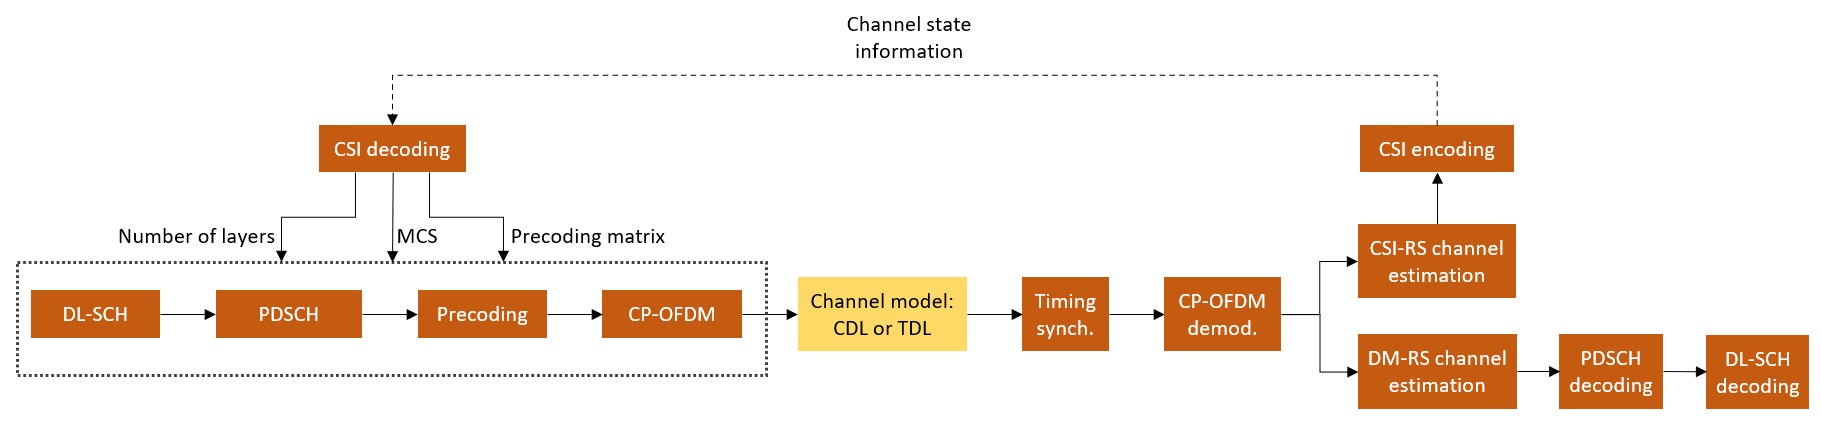

This simulation is based on the [NR PDSCH Throughput](docid:5g_ug#mw_new-radio-pdsch-throughput) example with the addition of using CSI feedback from the receiver to adjust transmission parameters.

### CSI Feedback and Link Adaptation in 5G NR

User equipment (UE) uses channel state information reference signals (CSI-RS) to estimate the downlink channel response and reports a set of CSI indicators. The CSI report includes these indicators, as defined in TS 38.214 Section 5.2.2:

- Rank indicator (RI)

- Precoding matrix indicator (PMI)

- Channel quality indicator (CQI)

The gNodeB uses the reported CSI to configure the target code rate, modulation, number of layers, and MIMO precoding matrix in subsequent PDSCH transmissions after a configurable delay. Generally, the gNodeB can select different transmission parameters from those a UE reports. However, in this simulation, the gNodeB strictly follows the recommendation from the UE. For more information on how the UE selects RI, PMI, and CQI, see the [5G NR Downlink CSI Reporting](docid:5g_ug#mw_d1f89a94-4ef9-4f57-9301-212f082e187e) example. 

### CSI Feedback and Link Adaptation Beyond 5G NR

You can use this simulation to explore other CSI techniques, such as the one described in [CSI Feedback with Autoencoders](docid:5g_ug#mw_bd0ec767-af55-4fb3-afec-751efab7be51). You can configure the UE to use an autoencoder AI neural network to encode channel estimates and feed back this form of CSI to the gNodeB. The gNodeB decodes this compressed CSI and adapts the target code rate, modulation, number of layers, and MIMO precoding matrix. The gNodeB selects the MIMO precoding matrix from the eigenvectors of the recovered channel estimates and a suitable modulation and coding scheme (MCS) from TS 38.214 Table 5.1.3.1-1, conditioned on the selected MIMO precoder. Finally, it applies the selected configuration in a subsequent PDSCH transmission after a configurable delay.

The simulation assumes these conditions for both forms of CSI feedback:

- No uplink transmissions. The CSI feedback is transmitted without errors from the UE to the gNodeB. 

- Fixed PDSCH PRB allocation for the length of the simulation. No scheduler exists to adapt the allocation to the channel conditions.

- FDD operation.

- No HARQ support.

## Simulation Length and SNR Points

Set the length of the simulation in terms of the number of 10 ms frames. To produce statistically meaningful throughput results, you must update the number of frames (`NFrames`) to a large number. Set the signal-to-noise ratio (SNR) points to simulate. The SNR for each layer is defined per resource element (RE) and includes the effect of signal and noise across all antennas. For an explanation of the SNR definition that this example uses, see the [SNR Definition used in Link Simulations](docid:5g_ug#mw_37cef3ca-2f4b-433d-8d68-117a881ca5fd) example.

simParameters = struct();       % Clear simParameters variable to contain all key simulation parameters 
% simParameters.NFrames = 5;      % Number of 10 ms frames
% simParameters.NFrames = 77057; %FULL RUN 0 -180
simParameters.NFrames = 38528; % HALF RUN 0-90

%BLKERR settings
BLER = 0; %set to zero until first frame CQI is reported
BLER_window = 2000 %= 1000 %BLER window = 100 slots. 

BLER_window = 2000

TargetBLER = 0.001

TargetBLER = 1.0000e-03

MCS_Allo = 0;

simParameters.SNRIn = [1]; % SNR range (dB)


## Channel Estimator Configuration

The logical variable `PerfectChannelEstimator` controls channel estimation and synchronization behavior. When this variable is set to `true`, the simulation uses perfect channel estimation and synchronization. When this variable is set to `false`, the simulation uses practical channel estimation and synchronization based on the values of the received PDSCH demodulation reference signal (DM-RS).

simParameters.PerfectChannelEstimator = false;

## Simulation Diagnostics

The variable `DisplaySimulationInformation` controls the display of simulation information.

simParameters.DisplaySimulationInformation = false;
simParameters.MakeTableInformation = 'True' ;

The `DisplayDiagnostics` flag enables the plotting of the error vector magnitude (EVM) per layer. This plot monitors the quality of the received signal after equalization. The EVM per layer figure shows:

- The EVM per layer per slot, which shows the EVM evolving with time.

- The EVM per layer per resource block, which shows the EVM in frequency.

This figure evolves with the simulation and is updated with each slot. Typically, low SNR or channel fades can result in decreased signal quality (high EVM). The channel affects each layer differently. Therefore, the EVM values can differ across layers.

simParameters.DisplayDiagnostics = false;

## Carrier and PDSCH Configuration

Set waveform type, PDSCH numerology (subcarrier spacing (SCS) and cyclic prefix (CP) type), and other transmission configuration parameters.

% SCS carrier parameters
simParameters.Carrier = nrCarrierConfig;         % Carrier resource grid configuration
simParameters.Carrier.NSizeGrid = 52;            % Bandwidth in number of resource blocks
simParameters.Carrier.SubcarrierSpacing = 15;    % 15, 30, 60, 120 (kHz)
simParameters.Carrier.CyclicPrefix = 'Normal';   % 'Normal' or 'Extended' (Extended CP is relevant for 60 kHz SCS only)
simParameters.Carrier.NCellID = 1;               % Cell identity

Specify a full-band slot-wise PDSCH transmission and reserve the first 2 OFDM symbols.

simParameters.PDSCH = nrPDSCHConfig;      % This PDSCH definition is the basis for all PDSCH transmissions in the simulation

% Define PDSCH time allocation in a slot
simParameters.PDSCH.MappingType = "A"; % PDSCH mapping type ('A'(slot-wise),'B'(non slot-wise))
symAlloc = [2 simParameters.Carrier.SymbolsPerSlot-2];  % Starting symbol and number of symbols of each PDSCH allocation
simParameters.PDSCH.SymbolAllocation = symAlloc;

% Define PDSCH frequency resource allocation per slot to be full grid 
simParameters.PDSCH.PRBSet = 0:simParameters.Carrier.NSizeGrid-1;

% Scrambling identifiers
simParameters.PDSCH.NID = simParameters.Carrier.NCellID;
simParameters.PDSCH.RNTI = 1;

Specify the DM-RS configuration, as defined in TS 38.211 Section 7.4.1.1. The DM-RS port set is dynamic and based on CSI feedback (RI).

simParameters.PDSCH.DMRS.DMRSTypeAPosition       = 2; % Mapping type A only. First DM-RS symbol position (2,3)
simParameters.PDSCH.DMRS.DMRSLength              = 1; % Number of front-loaded DM-RS symbols (1(single symbol),2(double symbol))
simParameters.PDSCH.DMRS.DMRSAdditionalPosition  = 2; % Additional DM-RS symbol positions (max range 0...3)
simParameters.PDSCH.DMRS.DMRSConfigurationType   = 2; % DM-RS configuration type (1,2)
simParameters.PDSCH.DMRS.NumCDMGroupsWithoutData = 3; % CDM groups without data (1,2,3)

Specify additional simulation parameters for the DL-SCH and PDSCH. Set the frequency granularity of the MIMO precoder, as defined in TS 38.214 Section 5.1.2.3, the modulation and coding scheme table, as defined in TS 38.214 Section 5.1.3.1, and the overhead for transport block size calculation. Set `XOverhead` to empty (`[]`) for automatic selection based on the CSI-RS allocated REs.

simParameters.PDSCHExtension = struct();
simParameters.PDSCHExtension.PRGBundleSize = 4; % 2, 4, or [] to signify "wideband"
simParameters.PDSCHExtension.MCSTable      = 'Table1'; % 'Table1',...,'Table4'
simParameters.PDSCHExtension.XOverhead     = [ ]; % 0, 6, 12, 18, or [] for automatic selection.

Configure the LDPC decoding algorithm and maximum LDPC iterations. The available decoding algorithms are '`Belief propagation`', '`Layered belief propagation`', '`Normalized min-sum`', and '`Offset min-sum`'.

simParameters.PDSCHExtension.LDPCDecodingAlgorithm = "Normalized min-sum";
simParameters.PDSCHExtension.MaximumLDPCIterationCount = 6;

## Antenna Panel Configuration

Configure the antenna panel geometry by specifying the number of antenna panels ($N_g$) and their dimensions ($N_1$ and $N_2$). $N_1$ and $N_2$ are the number of cross-polarized antenna elements in horizontal and vertical directions for each panel, respectively, and $N_g$ is the number of column array panels. This diagram shows an antenna panel arrangement and its dimensions. 

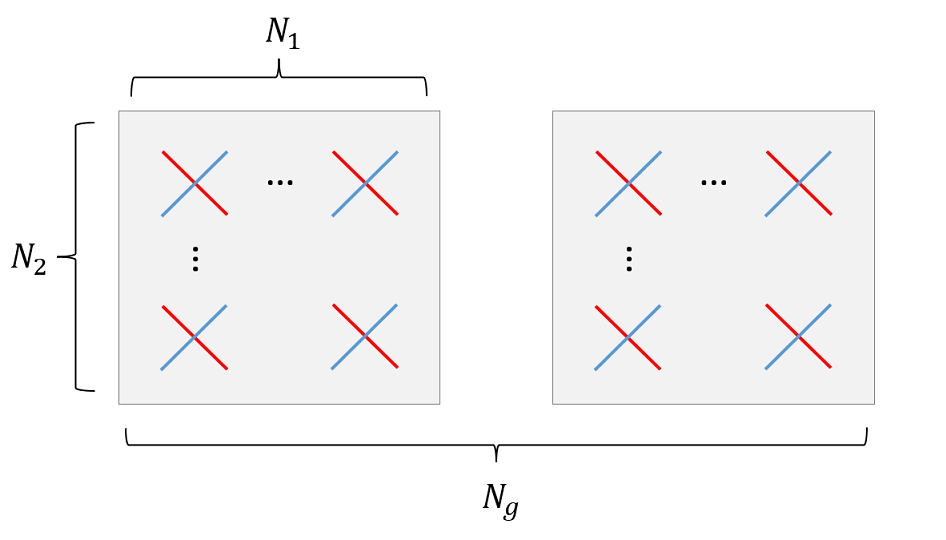

The MIMO precoding codebooks defined in TS 38.214 Section 5.2.2.2 restrict the values of $N_g$, $N_1$, and $N_2$ that 5G NR supports. To configure single-input single-output (SISO) transmissions with single-polarized antenna elements, set the panel dimensions to [1 1]. The receiver panel dimensions are not limited by the codebooks.

simParameters.TransmitAntennaArray.NumPanels        = 1; % Number of panels in horizontal dimension (Ng)
simParameters.TransmitAntennaArray.PanelDimensions  = [1,1]; % Number of columns and rows in a panel (N1, N2)
simParameters.ReceiveAntennaArray.NumPanels         = 1; % Number of panels in horizontal dimension (Ng)
simParameters.ReceiveAntennaArray.PanelDimensions   = [1 1];                % Number of columns and rows in a panel (N1, N2)


Due to polarization, the overall number of antennas is $2\times N_1 \times N_2 \times N_g$. 

simParameters.NTxAnts = numAntennaElements(simParameters.TransmitAntennaArray);
simParameters.NRxAnts = numAntennaElements(simParameters.ReceiveAntennaArray);

## CSI-RS Configuration

The simulation configures an 8-port CSI-RS, which maps to each antenna element of the transmit panel. The number of CSI-RS ports must match the transmit array panel's dimensions, as defined in TS 38.214 Table 5.2.2.2.1-2 for single-panel and Table 5.2.2.2.2-1 for multi-panel codebooks. These tables show what CSI-RS row numbers are compatible with the selected array panel dimensions.

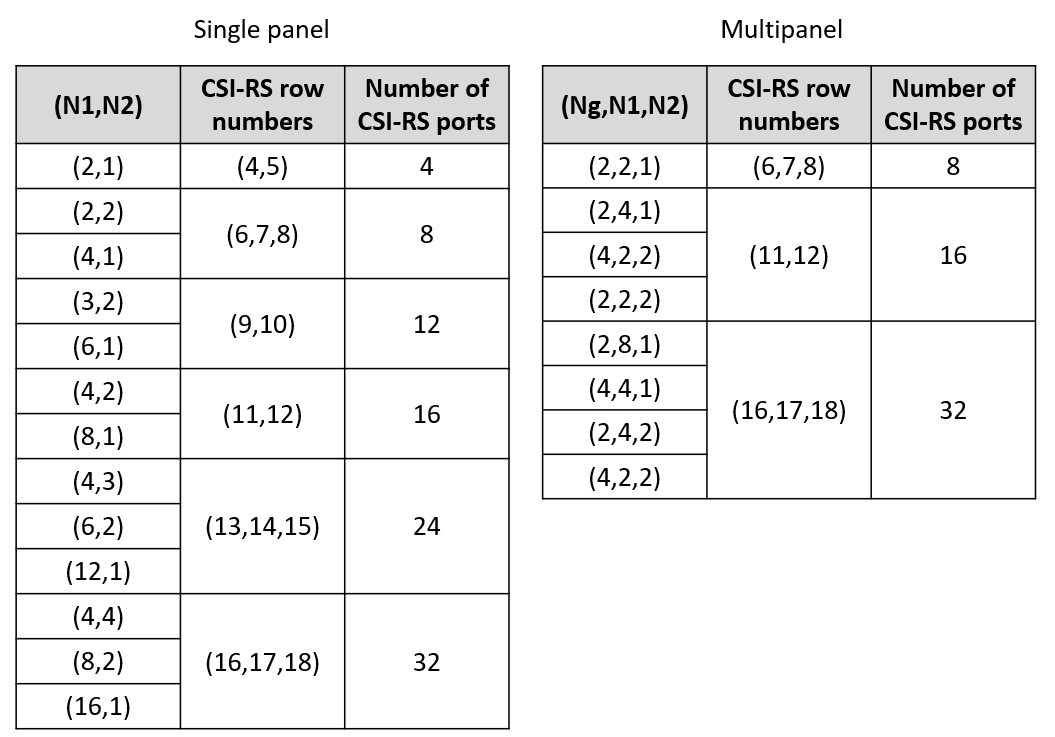

Configure the CSI-RS transmission parameters. 

simParameters.CSIRS = nrCSIRSConfig;
simParameters.CSIRS.CSIRSType = 'nzp'; % 'nzp','zp'
simParameters.CSIRS.RowNumber = 1; % 1...18
simParameters.CSIRS.NumRB = simParameters.Carrier.NSizeGrid - simParameters.CSIRS.RBOffset;
simParameters.CSIRS.CSIRSPeriod = [10 0];
simParameters.CSIRS.SymbolLocations = 4;
simParameters.CSIRS.SubcarrierLocations = [0];
simParameters.CSIRS.Density = 'three';

disp(['Number of CSI-RS ports: ' num2str(simParameters.CSIRS.NumCSIRSPorts) '.'])

Number of CSI-RS ports: 1.


csirsCDMLengths = getCSIRSCDMLengths(simParameters.CSIRS);

% Check that the number of CSI-RS ports and transmit antenna elements match
% and the consistency of multiple CSI-RS resources
validateCSIRSConfig(simParameters.Carrier,simParameters.CSIRS,simParameters.NTxAnts);

## CSI Feedback Configuration

Specify the CSI feedback mode as one of '`RI-PMI-CQI`', '`AI CSI compression`', or '`Perfect CSI`'. In all modes, the UE can perform perfect or practical channel estimation using CSI-RS.

- **RI-PMI-CQI**: The UE selects and reports the appropriate RI, PMI, and CQI periodically. The gNodeB follows the reported CSI to configure the target code rate, modulation, number of layers, and MIMO precoding matrix in subsequent transmissions after a configurable delay.

- **AI CSI compression**: The UE compresses channel estimates using an AI neural network autoencoder and reports them to the gNodeB periodically. The gNodeB recovers the channel estimates and selects appropriate target code rate, modulation, number of layers, and MIMO precoding matrix. The gNodeB applies the selected configuration in a subsequent PDSCH transmission after a configurable delay. You can specify the filename of the neural network. This simulation downloads a pretrained neural network that is valid only when the number of transmit antennas is 8 and a carrier grid size of 52 RB and 15 kHz subcarrier spacing. For other number of transmit antennas and bandwidths, you need to train the neural network as described in [CSI Feedback with Autoencoders](docid:5g_ug#mw_bd0ec767-af55-4fb3-afec-751efab7be51).

- **Perfect CSI**: The UE reports channel estimates to the gNodeB periodically. This mode is equivalent to the '`AI CSI compression`' mode without compression losses.

simParameters.CSIReportMode = 'RI-PMI-CQI'; % 'RI-PMI-CQI','AI CSI compression','Perfect CSI'

Specify the CSI report configuration. For more information on the CSI report configuration, see the [5G NR Downlink CSI Reporting](docid:5g_ug#mw_d1f89a94-4ef9-4f57-9301-212f082e187e) example.

simParameters.CSIReportConfig = struct();
simParameters.CSIReportConfig.Period = [5 0];  % Peridocity and offset of the CSI report in slots

if simParameters.CSIReportMode == "RI-PMI-CQI"  
    
    simParameters.CSIReportConfig.CQITable          = "Table3"; % 'Table1','Table2','Table3'
    simParameters.CSIReportConfig.CQIMode           = 'Wideband'; % 'Wideband','Subband'
    simParameters.CSIReportConfig.PMIMode           = 'Subband'; % 'Wideband','Subband'
    simParameters.CSIReportConfig.CodebookType      = 'Type1SinglePanel'; % 'Type1SinglePanel','Type1MultiPanel','Type2'
    simParameters.CSIReportConfig.SubbandSize       = 4; % Subband size in RB (4,8,16,32)
    simParameters.CSIReportConfig.CodebookMode      = 1; % 1,2
    simParameters.CSIReportConfig.RIRestriction     = [];                   % Empty for no rank restriction  
    simParameters.CSIReportConfig.NumberOfBeams     = 2; % 2,3,4. Only for Type II codebooks
    simParameters.CSIReportConfig.PhaseAlphabetSize = 8; % 4,8. Only for Type II codebooks
    simParameters.CSIReportConfig.SubbandAmplitude  = true;                  % true/false. Only for Type II codebooks
    simParameters.CSIReportConfig.NStartBWP         = [];                   % Empty to signal the entire carrier
    simParameters.CSIReportConfig.NSizeBWP          = [];                   % Empty to signal the entire carrier

    % Configure the CSI report with the antenna panel dimensions specified
    simParameters.CSIReportConfig.PanelDimensions = getCSIReportPanelDimensions(simParameters.TransmitAntennaArray,simParameters.CSIReportConfig.CodebookType);

else % AI CSI compression

    % Specify the file name of the AI neural network
    simParameters.AINetworkFilename = 'csiTrainedNetwork.mat'; 

end

Configure the CSI processing delay in slots. For the UE, this delay is the number of time slots between the reception of the CSI-RS and the availability of the CSI feedback. For the gNodeB, the delay is the number of time slots between the reception of the CSI report and the transmission using the recommended CSI.

simParameters.UEProcessingDelay = 7;
simParameters.BSProcessingDelay = 1;

## Propagation Channel Configuration

Configure the delay profile, delay spread, and maximum Doppler shift of the propagation channel for the simulation. Both CDL and TDL channel models are supported. The panel dimensions and cross-polarized elements specified in Antenna Panel Configuration define the geometry of the antenna arrays for CDL channels.

simParameters.DelayProfile = 'CDL-C';   % 'CDL-A',...,'CDL-E','TDL-A',...,'TDL-E'
simParameters.DelaySpread = 300e-9;     % s
simParameters.MaximumDopplerShift = 5;  % Hz

simParameters.SatelliteAltitude = 600e3;%(m)
simParameters.CarrierFrequency = 2e9;   %(Hz)
simParameters.ElevationAngle = 30;      %(deg)
% simParameters.txPowerdBm = 78.7;        %(dBm)
simParameters.txPowerdBm = 60;        %(dBm)

G = 6.67384e-11;
M = 5.97e24;
simParameters.SatelliteSpeed = sqrt((G*M)/(physconst('earthradius')+simParameters.SatelliteAltitude)   );
simParameters.Channel = createChannel(simParameters);
simParameters.RxNoiseFigure = 7;
simParameters.RxAntennaTemperature = 290;


## Print Parameters

Parameters to print to show at the beginning of a run:

fprintf("CQI Table:%s \n",simParameters.CSIReportConfig.CQITable );

CQI Table:Table3 


## Processing Loop

To determine the PDSCH throughput for each SNR point, the simulation performs these steps:

- Update DL-SCH and PDSCH transmission parameters (target code rate, number of layers, modulation, and MIMO precoding matrix). This step applies only when a new CSI report is available.

- Map CSI-RS signals to the resource grid.

- Perform channel coding (DL-SCH) and PDSCH encoding. Map PDSCH and PDSCH DM-RS to the resource grid.

- OFDM modulate the generated grid.

- Pass the signal through a fading channel with AWGN.

- Perform synchronization and OFDM demodulation.

- Perform PDSCH DM-RS based channel estimation.

- Perform equalization.

- Decode the PDSCH and DL-SCH, and measure the PDSCH throughput.

- Perform CSI-RS based channel estimation.

- Create CSI report.

- Feed the CSI report back to the transmitter with the appropriate delay.

To reduce the total simulation time, you can execute the SNR loop in parallel by using the Parallel Computing Toolbox™. Comment out the `for` statement and uncomment the `parfor` statement. If the Parallel Computing Toolbox is not installed, `parfor` defaults to normal `for` statement. Because parfor-loop iterations are executed in parallel in a nondeterministic order, the simulation information displayed for each SNR point can be intertwined. To switch off simulation information display, set the `displaySimulationInformation` variable above to false.

% Array to store the maximum throughput for all SNR points
maxThroughput = zeros(length(simParameters.SNRIn),1); 
% Array to store the simulation throughput for all SNR points
simThroughput = zeros(length(simParameters.SNRIn),1);
%store results to make a table later:

% Cell array to store CSI reports per SNR point
CSIReport = {};

for snrIdx = 1:numel(simParameters.SNRIn)
% parfor snrIdx = 1:numel(simParameters.SNRIn)
% To reduce the total simulation time, you can execute this loop in
% parallel by using the Parallel Computing Toolbox. Comment out the 'for'
% statement and uncomment the 'parfor' statement.
    
    % Reset the random number generator for repeatability
    rng(0,"twister");

    % Display simulation information at this SNR point
    % displaySNRPointProgress(simParameters,snrIdx);

    % Take full copies of the simulation-level parameter structures so that
    % they are not PCT broadcast variables when using parfor
    simParamLocal = simParameters;

    % Set up the transmitter, propagation channel, receiver, and CSI
    % feedback configuration parameters.
    [carrier,encodeDLSCH,pdsch,pdschextra,csirs,wtx] = setupTransmitter(simParamLocal);
    [channel,maxChDelay,N0] = setupChannel(simParamLocal,snrIdx);
    [decodeDLSCH,pathFilters,timingOffset] = setupReceiver(simParamLocal);
    csiFeedbackOpts = getCSIFeedbackOptions(simParamLocal,snrIdx);

    % Obtain an initial CSI report based on perfect channel estimates that
    % the Tx can use to adapt the transmission parameters.
    csiReports = initialCSIReport(simParamLocal,snrIdx,carrier,csirs,channel,csiFeedbackOpts);
    csiAvailableSlots = 0;

    % Total number of slots in the simulation period
    NSlots = simParamLocal.NFrames * carrier.SlotsPerFrame;
    
    %setup the results variables. Pre Allocating Speeds things up
    results     = zeros(length(NSlots-1),1);
    slot        = zeros(length(NSlots-1),1);
    slotPercnt  = zeros(length(NSlots-1),1);
    eleAnge     = zeros(length(NSlots-1),1);
    PathLoss    = zeros(length(NSlots-1),1);
    SNR         = zeros(length(NSlots-1),1);
    CQI_result  = zeros(length(NSlots-1),1);
    currentMCS  = zeros(length(NSlots-1),1);
    modOrder    = zeros(length(NSlots-1),1);
    TCR         = zeros(length(NSlots-1),1);
    ECR         = zeros(length(NSlots-1),1);
    BLKErr      = zeros(length(NSlots-1),1);
    BLER_results        = zeros(length(NSlots-1),1);
    transBlkSize      = zeros(length(NSlots-1),1);

    re = physconst("earthradius"); %  (m)
    c = physconst("lightspeed");   % (m/s)
    r_earth = 6371000; %(m)
    M_earth = 5.9720e+24;
    H = 600e3;
    h = simParamLocal.SatelliteAltitude;
    T = (2*pi*(r_earth+H)^(3/2))/(sqrt(G*M_earth));
    Lmax = 90 - rad2deg(asin((r_earth/(r_earth+H))*cos(0))    );
    CoverageTime = T*(Lmax/180); %(s)
    CoverageFrames = CoverageTime*100;
    CoverageSlots = CoverageFrames*10;
    %CoverageTime = CoverageTime/60 %(min)
    eleTicPerSlot = 180 /CoverageSlots;

    
    % Loop over the entire waveform length
    for nslot = 0:NSlots-1
%%%
        %[snr] = computeSNR(simParamLocal,nslot);
        [channel,maxChDelay,N0] = setupChannel(simParamLocal,snrIdx);
        % Update the carrier slot numbers for new slot
        carrier.NSlot = nslot;


        %update for the BlkERR
        if nslot >0  && nslot<= BLER_window
            BLER = sum(BLKErr(1:nslot))/nslot;
            % fprintf("xBLER:%.4f %d \n",BLER,nslot)
        elseif nslot > 0
            s = nslot-BLER_window;
            BLER = sum(BLKErr(s:nslot)) / BLER_window;
        end
        % fprintf("BLER:%.4f\n",BLER)

        % Use new CSI report to configure the number of layers and
        % modulation of the PDSCH and target code rate of the DL-SCH if
        % there is a new report available.
        [isNewReport,repIdx] = ismember(nslot,csiAvailableSlots);
        if isNewReport
            
            % [pdsch.Modulation,Qm,pdschextra.TargetCodeRate,MCS_Allo,wtx] = hCSIDecode(carrier,pdsch,pdschextra,csiReports(repIdx),csiFeedbackOpts);
            
            [pdsch.Modulation,Qm,pdschextra.TargetCodeRate,MCS_Allo,wtx] = MCS_Allo_Algo1(carrier,pdsch,pdschextra,csiReports(repIdx),csiFeedbackOpts,BLER,TargetBLER,MCS_Allo(:,1));


            pdsch.NumLayers = size(wtx,1);
            encodeDLSCH.TargetCodeRate = pdschextra.TargetCodeRate;
        end

        % Create an OFDM resource grid for a slot
        dlGrid = nrResourceGrid(carrier,csirs.NumCSIRSPorts);

        % CSI-RS mapping to the slot resource grid
        [csirsInd,csirsInfo] = nrCSIRSIndices(carrier,csirs);
        csirsSym = nrCSIRS(carrier,csirs);
        dlGrid(csirsInd) = csirsSym;
        csirsTransmission = ~isempty(csirsInd);

        % PDSCH reserved REs for CSI-RS
        pdsch.ReservedRE = csirsInd-1; % 0-based indices
        
        % PDSCH generation
        % Calculate the transport block sizes for the transmission in the slot
        [pdschIndices,pdschIndicesInfo] = nrPDSCHIndices(carrier,pdsch);
        trBlkSizes = nrTBS(pdsch.Modulation,pdsch.NumLayers,numel(pdsch.PRBSet),pdschIndicesInfo.NREPerPRB,pdschextra.TargetCodeRate,pdschextra.XOverhead);

        % Transport block generation
        for cwIdx = 1:pdsch.NumCodewords
            % New data for current codeword then create a new DL-SCH transport block
            trBlk = randi([0 1],trBlkSizes(cwIdx),1);
            setTransportBlock(encodeDLSCH,trBlk,cwIdx-1);
            resetSoftBuffer(decodeDLSCH,cwIdx-1);
        end

        % Encode the DL-SCH transport blocks
        RV = zeros(1,pdsch.NumCodewords);
        codedTrBlocks = encodeDLSCH(pdsch.Modulation,pdsch.NumLayers, ...
            pdschIndicesInfo.G,RV);

        % PDSCH modulation and precoding
        pdschSymbols = nrPDSCH(carrier,pdsch,codedTrBlocks);
        [pdschAntSymbols,pdschAntIndices] = nrPDSCHPrecode(carrier,pdschSymbols,pdschIndices,wtx);
        dlGrid(pdschAntIndices) = pdschAntSymbols;        

        % PDSCH DM-RS precoding and mapping
        dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
        dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);
        [dmrsAntSymbols,dmrsAntIndices] = nrPDSCHPrecode(carrier,dmrsSymbols,dmrsIndices,1);
        dlGrid(dmrsAntIndices) = dmrsAntSymbols;

        % OFDM modulation
        txWaveform0 = nrOFDMModulate(carrier,dlGrid);

        % Scale the waveform power based on the input transmit power
        wavePower = 10*log10(sum(var(txWaveform0)));
        powerScaling = (simParamLocal.txPowerdBm-30)-wavePower;      % In dB
        txWaveform = db2mag(powerScaling)*txWaveform0;
        % fprintf("txWaveForm0:%.2f wxWaveform1:%.2f",10*log10(sum(var(txWaveform0))),10*log10(sum(var(txWaveform)))    )
        % Apply Doppler pre-compensation depending on DopplerPreCompensator
        % txWaveform = compensateDopplerShift(...
        % txWaveform,ntnChanLocal.BaseChannel.SampleRate, ...
        % preDopplerShift,simLocal.DopplerPreCompensator);

        %compute pathloss to the model:
        elevAngle = nslot*eleTicPerSlot;
        slantDist = -re*sind(elevAngle) + sqrt((re*sind(elevAngle)).^2 + h*h + 2*re*h);
        lambda = c/simParamLocal.CarrierFrequency;
        pathLoss = fspl(slantDist,lambda); % in dB
        PL_dBint = pathLoss;
        %fprintf("\n fspl:%.6f \n",pathLoss);
        

        %apply Pathloss to the txWaveForm
        nSubFrames = 10;
        samples = 0;
        subframeTimes = (0:(simParamLocal.NFrames*nSubFrames)-1)*1e-3;
        slotTimes = cast(reshape(samples+subframeTimes,[],1),'double');
        pathLoss = repmat(pathLoss,1,numel(slotTimes));
        txWaveform = txWaveform*db2mag(-pathLoss(carrier.NSlot+1));
        % fprintf(" txWaveform2:%.2f",10*log10(sum(var(txWaveform))))
        % Apply fixed or static delay
        simParamLocal.DelayModel = "None";
        if simParamLocal.DelayModel == "None"
            staticDelay = dsp.Delay(Length=0);
            variableIntegerDelay = 0;
            variableFractionalDelay = 0;
            delayInSeconds = 0;
            delayedTx = staticDelay(txWaveform);
        end
        % Apply variable integer delay
        if isa(variableIntegerDelay,"dsp.VariableIntegerDelay")
            delayedTx = variableIntegerDelay(delayedTx,varIntegSamples(carrier.NSlot+1));
        end
        % Apply variable fractional delay
        if isa(variableFractionalDelay,"dsp.VariableFractionalDelay")
            delayedTx = variableFractionalDelay(delayedTx,varFracSamples(carrier.NSlot+1));
        end

        % Pass the waveform through the channel
        % txWaveform = delayedTx;
        % [rxWaveform,pathGains] = HelperGenerateNTNChannel(...
        %     ntnChanLocal,txWaveform);
        
        % Pass data through channel model. Append zeros at the end of the
        % transmitted waveform to flush channel content. These zeros take
        % into account any delay introduced in the channel.
        txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))]; %#ok<AGROW>
        [rxWaveform,pathGains,sampleTimes] = channel(txWaveform);
        % fprintf(" rxWaveForm:%.2f",10*log10(sum(var(rxWaveform))))
        % Add AWGN to the received time-domain waveform
        noise = N0*complex(randn(size(rxWaveform)),randn(size(rxWaveform)));
        snrSlot = snr(rxWaveform,noise);
        rxWaveform = rxWaveform + noise;

        if (simParamLocal.PerfectChannelEstimator)
            % Perfect synchronization. Use information provided by the
            % channel to find the strongest multipath component
            pathFilters = getPathFilters(channel);
            [timingOffset,mag] = nrPerfectTimingEstimate(pathGains,pathFilters);
        else
            % Practical synchronization. Correlate the received waveform
            % with the PDSCH DM-RS to obtain the timing offset and
            % correlation magnitude. The receiver updates the timing offset
            % only when the correlation magnitude is high.
            [t,mag] = nrTimingEstimate(carrier,rxWaveform,dmrsIndices,dmrsSymbols); 
            timingOffset = hSkipWeakTimingOffset(timingOffset,t,mag);
            % Display a warning if the estimated timing offset exceeds the
            % maximum channel delay
            if timingOffset > maxChDelay
                warning(['Estimated timing offset (%d) is greater than the maximum channel delay (%d).' ...
                    ' This will result in a decoding failure. This may be caused by low SNR,' ...
                    ' or not enough DM-RS symbols to synchronize successfully.'],timingOffset,maxChDelay);
            end
        end
        rxWaveform = rxWaveform(1+timingOffset:end,:);

        % Perform OFDM demodulation on the received data to recreate the
        % resource grid, including padding in the event that practical
        % synchronization results in an incomplete slot being demodulated
        rxGrid = nrOFDMDemodulate(carrier,rxWaveform);
        [K,L,R] = size(rxGrid);
        if (L < carrier.SymbolsPerSlot)
            rxGrid = cat(2,rxGrid,zeros(K,carrier.SymbolsPerSlot-L,R));
        end

        if (simParamLocal.PerfectChannelEstimator)
            % Perfect channel estimation, using the value of the path gains
            % provided by the channel. This channel estimate does not
            % include the effect of transmitter precoding
            Hest = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,timingOffset,sampleTimes);

            % Get perfect noise estimate (from the noise realization)
            noiseGrid = nrOFDMDemodulate(carrier,noise(1+timingOffset:end ,:));
            noiseEst = var(noiseGrid(:));

            % Get PDSCH resource elements from the received grid and 
            % channel estimate
            [pdschRx,pdschHest,~,pdschHestIndices] = nrExtractResources(pdschIndices,rxGrid,Hest);

            % Apply precoding to channel estimate
            pdschHest = nrPDSCHPrecode(carrier,pdschHest,pdschHestIndices,permute(wtx,[2 1 3]));
        else
            % Practical channel estimation between the received grid and
            % each transmission layer, using the PDSCH DM-RS for each
            % layer. This channel estimate includes the effect of
            % transmitter precoding
            [Hest,noiseEst] = hSubbandChannelEstimate(carrier,rxGrid,dmrsIndices,dmrsSymbols,pdschextra.PRGBundleSize,'CDMLengths',pdsch.DMRS.CDMLengths);

            % Average noise estimate across PRGs and layers
            noiseEst = mean(noiseEst,'all');
            
            % Get PDSCH resource elements from the received grid and
            % channel estimate
            [pdschRx,pdschHest] = nrExtractResources(pdschIndices,rxGrid,Hest);
        end

        % Equalization
        [pdschEq,eqCSIScaling] = nrEqualizeMMSE(pdschRx,pdschHest,noiseEst);

        % Decode PDSCH physical channel
        [dlschLLRs,rxSymbols] = nrPDSCHDecode(carrier,pdsch,pdschEq,noiseEst);
        
        % Display EVM per layer, per slot and per RB
        if (simParamLocal.DisplayDiagnostics)
            plotLayerEVM(NSlots,nslot,pdsch,size(dlGrid),pdschIndices,pdschSymbols,pdschEq);
        end
        
        % Scale LLRs
        eqCSIScaling = nrLayerDemap(eqCSIScaling); % CSI scaling layer demapping
        for cwIdx = 1:pdsch.NumCodewords
            Qm = length(dlschLLRs{cwIdx})/length(rxSymbols{cwIdx});        % bits per symbol
            eqCSIScaling{cwIdx} = repmat(eqCSIScaling{cwIdx}.',Qm,1);      % expand by each bit per symbol
            dlschLLRs{cwIdx} = dlschLLRs{cwIdx} .* eqCSIScaling{cwIdx}(:); % scale LLRs
        end
        
        % Decode the DL-SCH transport channel
        decodeDLSCH.TransportBlockLength = trBlkSizes;
        decodeDLSCH.TargetCodeRate = pdschextra.TargetCodeRate;
        [decbits,blkerr] = decodeDLSCH(dlschLLRs,pdsch.Modulation,pdsch.NumLayers,RV);
        
        % Store values to calculate throughput
        % simThroughput(snrIdx) = simThroughput(snrIdx) + sum(~blkerr .* trBlkSizes);
        % maxThroughput(snrIdx) = maxThroughput(snrIdx) + sum(trBlkSizes);

        % CSI measurements and encoding 
        if csirsTransmission
            
            if (~simParamLocal.PerfectChannelEstimator)
                % Consider only the NZP-CSI-RS symbols and indices for CSI-RS based
                % channel estimation
                nzpind = (csirsSym ~= 0);
                
                % Calculate practical channel estimate based on CSI-RS. Use
                % a time-averaging window that covers all of the
                % transmitted CSI-RS symbols.
                [Hest,noiseEst] = nrChannelEstimate(carrier,rxGrid, ...
                    csirsInd(nzpind),csirsSym(nzpind),'CDMLengths',csirsCDMLengths);
            end

            % Generate CSI report. Store the report for use at the
            % transmitter. The CSI feedback is subject to a delay that
            % depends on the CSI report periodicity and the UE processing
            % delay. The slot in which the CSI is available to use at the
            % transmitter depends on the BS processing delay as well.
            rxCSIReport = hCSIEncode(carrier,csirs,Hest,noiseEst,csiFeedbackOpts);
            csiFeedbackSlot = nextCSISlot(csiFeedbackOpts.CSIReportPeriod,1+nslot+simParamLocal.UEProcessingDelay);
            csiAvailableSlots(end+1) = 1+csiFeedbackSlot+simParamLocal.BSProcessingDelay; %#ok<SAGROW>
            csiReports(end+1) = rxCSIReport; %#ok<SAGROW>
        end

        % Print slot-wise information
        if (simParamLocal.DisplaySimulationInformation)
            printSlotInfo(NSlots,carrier,pdsch,pdschextra,blkerr,trBlkSizes./pdschIndicesInfo.G,csirsTransmission,csiReports,repIdx,PL_dBint,elevAngle,snrSlot)
        end
        if (simParamLocal.MakeTableInformation)
           results = tableSlotInfo(NSlots,carrier,pdsch,pdschextra,blkerr,trBlkSizes./pdschIndicesInfo.G,csirsTransmission,csiReports,repIdx,PL_dBint,elevAngle,snrSlot);
            idx = nslot +1;
            slot(idx) = results.nslot ;
            slotPercnt(idx) = results.nslotPercnt ;
            eleAnge(idx) = results.eleAngle ;
            PathLoss(idx) = results.PathLoss ;
            SNR(idx) = results.SNR ;
            CQI_result(idx) = results.CQI_slot;
            currentMCS(idx) = MCS_Allo(:,1);
            modOrder(idx) = Qm ;
            TCR(idx) = results.TCR ;
            ECR(idx) = results.ECR ;
            BLKErr(idx) = blkerr;
            BLER_results(idx) = BLER;
            transBlkSize(idx) = trBlkSizes;
            
            if(mod(idx,50) == true)
            fprintf("\nslotPercnt:%3.3f slot:%6d eleAnge:%3.4f PathLoss:%3.4f SNR:%1.4f CQI:%2d MCS:%2d MOD:%2d TCR:%.4f TBS:%4d BLKErr:%d BLER:%.4f",...
                slotPercnt(idx),slot(idx),eleAnge(idx),PathLoss(idx),SNR(idx),CQI_result(idx),currentMCS(idx),modOrder(idx),TCR(idx),transBlkSize(idx),BLKErr(idx),BLER );
            end
        end
    
        modValue =1000;
        if mod(nslot,modValue) == 1 && nslot>5
            tocT = toc;
            seconds_remaining = (tocT/modValue)*(NSlots-1-nslot) ;
            fprintf("\n Ellapsed Time for %d frames: %.1f(s) Est Remaining:%.1f(s) %.2f(min) %.2(hr)",modValue,tocT,seconds_remaining,seconds_remaining/60,seconds_remaining/60/60   )
            
            tic
        end

    end  %for nslot:
    toc
    resultsTable = table(slotPercnt',slot',eleAnge',PathLoss',SNR',CQI_result',currentMCS',modOrder',TCR',transBlkSize',BLKErr',BLER_results',...
        VariableNames=["slotPercnt","slot","eleAnge","PathLoss","SNR","CQI","MCS","MOD","TCR","TBS","BLKErr","BLER"])
    time = string(datetime('now','Format','yyMMdd_HHmmss'));
    tableName_arry = ["ML_poly" + ...
        "_Case9_MCS_ThroughputCalulation_",".csv"];
    % BLER_window = 20;
    % TargetBLER = 0.05
    tableName = join(tableName_arry,'')
    writetable(resultsTable,tableName)
    % Store CSI report for each SNR point
    CSIReport{snrIdx} = csiReports; %#ok<SAGROW>
    
    % Display the results dynamically in the command window
    if (simParamLocal.DisplaySimulationInformation)
        fprintf('\n');
    end
    fprintf('\nThroughput(Mbps) for %d frame(s) = %.4f\n',...
        simParamLocal.NFrames,1e-6*simThroughput(snrIdx)/(simParamLocal.NFrames*10e-3)...
                                     ...
        );

end


slotPercnt:0.000 slot:     0 eleAnge:0.0000 PathLoss:167.5021 SNR:-8.2728 CQI: 8 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:1 BLER:0.0000
slotPercnt:0.013 slot:    50 eleAnge:0.0117 PathLoss:167.4981 SNR:-8.4292 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.2400
slotPercnt:0.026 slot:   100 eleAnge:0.0234 PathLoss:167.4941 SNR:-8.3707 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.1200
slotPercnt:0.039 slot:   150 eleAnge:0.0350 PathLoss:167.4901 SNR:-8.3821 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.1400
slotPercnt:0.052 slot:   200 eleAnge:0.0467 PathLoss:167.4862 SNR:-8.4438 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.1450
slotPercnt:0.065 slot:   250 eleAnge:0.0584 PathLoss:167.4822 SNR:-8.3266 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.1200
slotPercnt:0.078 slot:   300 eleAnge:0.0701 PathLoss:167.4782 SNR:-8.3285 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.1000
slotPercnt:0.091 slot:   350 eleAnge:0.0818 Pat


 Ellapsed Time for 1000 frames: 1733.0(s) Est Remaining:665936.3(s) 11098.94(min) 


slotPercnt:0.273 slot:  1050 eleAnge:0.2453 PathLoss:167.4184 SNR:-8.3539 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0438
slotPercnt:0.286 slot:  1100 eleAnge:0.2569 PathLoss:167.4144 SNR:-8.3106 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0418
slotPercnt:0.299 slot:  1150 eleAnge:0.2686 PathLoss:167.4104 SNR:-8.2842 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0400
slotPercnt:0.312 slot:  1200 eleAnge:0.2803 PathLoss:167.4064 SNR:-8.2897 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0383
slotPercnt:0.325 slot:  1250 eleAnge:0.2920 PathLoss:167.4024 SNR:-8.3073 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0368
slotPercnt:0.338 slot:  1300 eleAnge:0.3037 PathLoss:167.3985 SNR:-8.2827 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0354
slotPercnt:0.351 slot:  1350 eleAnge:0.3153 PathLoss:167.3945 SNR:-8.2358 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0341
slotPercnt:0.364 slot:  1400 eleAnge:0.3270 Pat


 Ellapsed Time for 1000 frames: 32.7(s) Est Remaining:12518.6(s) 208.64(min) 


slotPercnt:0.532 slot:  2050 eleAnge:0.4788 PathLoss:167.3387 SNR:-8.2143 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0170
slotPercnt:0.545 slot:  2100 eleAnge:0.4905 PathLoss:167.3347 SNR:-8.2244 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0170
slotPercnt:0.558 slot:  2150 eleAnge:0.5022 PathLoss:167.3307 SNR:-8.3049 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0125
slotPercnt:0.571 slot:  2200 eleAnge:0.5139 PathLoss:167.3267 SNR:-8.1836 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0120
slotPercnt:0.584 slot:  2250 eleAnge:0.5256 PathLoss:167.3227 SNR:-8.1503 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0110
slotPercnt:0.597 slot:  2300 eleAnge:0.5372 PathLoss:167.3187 SNR:-8.1128 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0110
slotPercnt:0.610 slot:  2350 eleAnge:0.5489 PathLoss:167.3147 SNR:-8.1874 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0110
slotPercnt:0.623 slot:  2400 eleAnge:0.5606 Pat


 Ellapsed Time for 1000 frames: 32.6(s) Est Remaining:12463.9(s) 207.73(min) 


slotPercnt:0.792 slot:  3050 eleAnge:0.7124 PathLoss:167.2589 SNR:-8.1244 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0070
slotPercnt:0.805 slot:  3100 eleAnge:0.7241 PathLoss:167.2550 SNR:-8.1299 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0070
slotPercnt:0.818 slot:  3150 eleAnge:0.7358 PathLoss:167.2510 SNR:-8.1008 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0100
slotPercnt:0.831 slot:  3200 eleAnge:0.7475 PathLoss:167.2470 SNR:-8.1369 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0120
slotPercnt:0.844 slot:  3250 eleAnge:0.7591 PathLoss:167.2430 SNR:-8.0588 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0120
slotPercnt:0.857 slot:  3300 eleAnge:0.7708 PathLoss:167.2390 SNR:-8.1674 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0120
slotPercnt:0.870 slot:  3350 eleAnge:0.7825 PathLoss:167.2350 SNR:-8.1220 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0120
slotPercnt:0.883 slot:  3400 eleAnge:0.7942 Pat


 Ellapsed Time for 1000 frames: 32.6(s) Est Remaining:12437.4(s) 207.29(min) 


slotPercnt:1.051 slot:  4050 eleAnge:0.9460 PathLoss:167.1793 SNR:-8.0975 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0145
slotPercnt:1.064 slot:  4100 eleAnge:0.9577 PathLoss:167.1753 SNR:-8.0520 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0145
slotPercnt:1.077 slot:  4150 eleAnge:0.9694 PathLoss:167.1713 SNR:-8.0636 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0145
slotPercnt:1.090 slot:  4200 eleAnge:0.9810 PathLoss:167.1673 SNR:-8.0228 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0115
slotPercnt:1.103 slot:  4250 eleAnge:0.9927 PathLoss:167.1633 SNR:-8.0496 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0115
slotPercnt:1.116 slot:  4300 eleAnge:1.0044 PathLoss:167.1593 SNR:-7.9970 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0115
slotPercnt:1.129 slot:  4350 eleAnge:1.0161 PathLoss:167.1554 SNR:-8.0922 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0115
slotPercnt:1.142 slot:  4400 eleAnge:1.0278 Pat


 Ellapsed Time for 1000 frames: 32.7(s) Est Remaining:12431.9(s) 207.20(min) 


slotPercnt:1.311 slot:  5050 eleAnge:1.1796 PathLoss:167.0996 SNR:-7.9199 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0095
slotPercnt:1.324 slot:  5100 eleAnge:1.1913 PathLoss:167.0956 SNR:-7.9903 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0095
slotPercnt:1.337 slot:  5150 eleAnge:1.2029 PathLoss:167.0916 SNR:-7.9783 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0065
slotPercnt:1.350 slot:  5200 eleAnge:1.2146 PathLoss:167.0877 SNR:-7.9324 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0045
slotPercnt:1.363 slot:  5250 eleAnge:1.2263 PathLoss:167.0837 SNR:-7.9529 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0045
slotPercnt:1.376 slot:  5300 eleAnge:1.2380 PathLoss:167.0797 SNR:-8.0041 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0045
slotPercnt:1.389 slot:  5350 eleAnge:1.2497 PathLoss:167.0757 SNR:-7.9585 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0045
slotPercnt:1.402 slot:  5400 eleAnge:1.2613 Pat


 Ellapsed Time for 1000 frames: 32.3(s) Est Remaining:12265.5(s) 204.42(min) 


slotPercnt:1.571 slot:  6050 eleAnge:1.4132 PathLoss:167.0200 SNR:-7.8756 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0045
slotPercnt:1.584 slot:  6100 eleAnge:1.4248 PathLoss:167.0160 SNR:-7.9472 CQI: 0 MCS: 1 MOD: 2 TCR:0.0293 TBS: 304 BLKErr:0 BLER:0.0045
slotPercnt:1.597 slot:  6150 eleAnge:1.4365 PathLoss:167.0120 SNR:-7.9205 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0045
slotPercnt:1.609 slot:  6200 eleAnge:1.4482 PathLoss:167.0081 SNR:-7.8513 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0045
slotPercnt:1.622 slot:  6250 eleAnge:1.4599 PathLoss:167.0041 SNR:-7.8945 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0045
slotPercnt:1.635 slot:  6300 eleAnge:1.4716 PathLoss:167.0001 SNR:-7.8882 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0045
slotPercnt:1.648 slot:  6350 eleAnge:1.4832 PathLoss:166.9961 SNR:-7.8741 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0045
slotPercnt:1.661 slot:  6400 eleAnge:1.4949 Pat


 Ellapsed Time for 1000 frames: 32.6(s) Est Remaining:12345.7(s) 205.76(min) 


slotPercnt:1.830 slot:  7050 eleAnge:1.6468 PathLoss:166.9404 SNR:-7.7894 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:1.843 slot:  7100 eleAnge:1.6584 PathLoss:166.9365 SNR:-7.7556 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0050
slotPercnt:1.856 slot:  7150 eleAnge:1.6701 PathLoss:166.9325 SNR:-7.7363 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0055
slotPercnt:1.869 slot:  7200 eleAnge:1.6818 PathLoss:166.9285 SNR:-7.8371 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0055
slotPercnt:1.882 slot:  7250 eleAnge:1.6935 PathLoss:166.9245 SNR:-7.8632 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0055
slotPercnt:1.895 slot:  7300 eleAnge:1.7051 PathLoss:166.9206 SNR:-7.7479 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0055
slotPercnt:1.908 slot:  7350 eleAnge:1.7168 PathLoss:166.9166 SNR:-7.8298 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0055
slotPercnt:1.921 slot:  7400 eleAnge:1.7285 Pat


 Ellapsed Time for 1000 frames: 32.8(s) Est Remaining:12375.3(s) 206.26(min) 


slotPercnt:2.090 slot:  8050 eleAnge:1.8803 PathLoss:166.8609 SNR:-7.7151 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0065
slotPercnt:2.103 slot:  8100 eleAnge:1.8920 PathLoss:166.8570 SNR:-7.6948 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0065
slotPercnt:2.116 slot:  8150 eleAnge:1.9037 PathLoss:166.8530 SNR:-7.7400 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0065
slotPercnt:2.129 slot:  8200 eleAnge:1.9154 PathLoss:166.8490 SNR:-7.6896 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0065
slotPercnt:2.142 slot:  8250 eleAnge:1.9271 PathLoss:166.8450 SNR:-7.7443 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0070
slotPercnt:2.155 slot:  8300 eleAnge:1.9387 PathLoss:166.8411 SNR:-7.7327 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0070
slotPercnt:2.168 slot:  8350 eleAnge:1.9504 PathLoss:166.8371 SNR:-7.6447 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0070
slotPercnt:2.180 slot:  8400 eleAnge:1.9621 Pat


 Ellapsed Time for 1000 frames: 32.9(s) Est Remaining:12393.7(s) 206.56(min) 


slotPercnt:2.349 slot:  9050 eleAnge:2.1139 PathLoss:166.7815 SNR:-7.6496 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:2.362 slot:  9100 eleAnge:2.1256 PathLoss:166.7775 SNR:-7.6539 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0050
slotPercnt:2.375 slot:  9150 eleAnge:2.1373 PathLoss:166.7735 SNR:-7.6587 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0045
slotPercnt:2.388 slot:  9200 eleAnge:2.1490 PathLoss:166.7696 SNR:-7.6116 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0045
slotPercnt:2.401 slot:  9250 eleAnge:2.1606 PathLoss:166.7656 SNR:-7.6448 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0045
slotPercnt:2.414 slot:  9300 eleAnge:2.1723 PathLoss:166.7616 SNR:-7.6728 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0045
slotPercnt:2.427 slot:  9350 eleAnge:2.1840 PathLoss:166.7577 SNR:-7.6168 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0045
slotPercnt:2.440 slot:  9400 eleAnge:2.1957 Pat


 Ellapsed Time for 1000 frames: 32.9(s) Est Remaining:12340.5(s) 205.68(min) 


slotPercnt:2.609 slot: 10050 eleAnge:2.3475 PathLoss:166.7021 SNR:-7.5370 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0015
slotPercnt:2.622 slot: 10100 eleAnge:2.3592 PathLoss:166.6982 SNR:-7.6009 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0015
slotPercnt:2.635 slot: 10150 eleAnge:2.3709 PathLoss:166.6942 SNR:-7.5276 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0015
slotPercnt:2.648 slot: 10200 eleAnge:2.3825 PathLoss:166.6902 SNR:-7.6110 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0015
slotPercnt:2.661 slot: 10250 eleAnge:2.3942 PathLoss:166.6863 SNR:-7.5498 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0010
slotPercnt:2.674 slot: 10300 eleAnge:2.4059 PathLoss:166.6823 SNR:-7.5694 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0010
slotPercnt:2.687 slot: 10350 eleAnge:2.4176 PathLoss:166.6783 SNR:-7.4747 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0010
slotPercnt:2.700 slot: 10400 eleAnge:2.4293 Pat


 Ellapsed Time for 1000 frames: 32.9(s) Est Remaining:12300.2(s) 205.00(min) 


slotPercnt:2.868 slot: 11050 eleAnge:2.5811 PathLoss:166.6228 SNR:-7.4882 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0010
slotPercnt:2.881 slot: 11100 eleAnge:2.5928 PathLoss:166.6189 SNR:-7.5345 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0010
slotPercnt:2.894 slot: 11150 eleAnge:2.6044 PathLoss:166.6149 SNR:-7.4702 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:2.907 slot: 11200 eleAnge:2.6161 PathLoss:166.6109 SNR:-7.5041 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0010
slotPercnt:2.920 slot: 11250 eleAnge:2.6278 PathLoss:166.6070 SNR:-7.5292 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0010
slotPercnt:2.933 slot: 11300 eleAnge:2.6395 PathLoss:166.6030 SNR:-7.4737 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0010
slotPercnt:2.946 slot: 11350 eleAnge:2.6512 PathLoss:166.5991 SNR:-7.5266 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0010
slotPercnt:2.959 slot: 11400 eleAnge:2.6628 Pat


 Ellapsed Time for 1000 frames: 32.7(s) Est Remaining:12222.8(s) 203.71(min) 


slotPercnt:3.128 slot: 12050 eleAnge:2.8147 PathLoss:166.5436 SNR:-7.4536 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0005
slotPercnt:3.141 slot: 12100 eleAnge:2.8263 PathLoss:166.5397 SNR:-7.3864 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0005
slotPercnt:3.154 slot: 12150 eleAnge:2.8380 PathLoss:166.5357 SNR:-7.4653 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0005
slotPercnt:3.167 slot: 12200 eleAnge:2.8497 PathLoss:166.5318 SNR:-7.4659 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0005
slotPercnt:3.180 slot: 12250 eleAnge:2.8614 PathLoss:166.5278 SNR:-7.3922 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0005
slotPercnt:3.193 slot: 12300 eleAnge:2.8731 PathLoss:166.5238 SNR:-7.4533 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0005
slotPercnt:3.206 slot: 12350 eleAnge:2.8847 PathLoss:166.5199 SNR:-7.3619 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0005
slotPercnt:3.219 slot: 12400 eleAnge:2.8964 Pat


 Ellapsed Time for 1000 frames: 33.3(s) Est Remaining:12414.6(s) 206.91(min) 


slotPercnt:3.387 slot: 13050 eleAnge:3.0482 PathLoss:166.4645 SNR:-7.3378 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0005
slotPercnt:3.400 slot: 13100 eleAnge:3.0599 PathLoss:166.4606 SNR:-7.3374 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0005
slotPercnt:3.413 slot: 13150 eleAnge:3.0716 PathLoss:166.4566 SNR:-7.4084 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0005
slotPercnt:3.426 slot: 13200 eleAnge:3.0833 PathLoss:166.4527 SNR:-7.2837 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0005
slotPercnt:3.439 slot: 13250 eleAnge:3.0950 PathLoss:166.4487 SNR:-7.2740 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0005
slotPercnt:3.452 slot: 13300 eleAnge:3.1066 PathLoss:166.4448 SNR:-7.2832 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0005
slotPercnt:3.465 slot: 13350 eleAnge:3.1183 PathLoss:166.4408 SNR:-7.2719 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0005
slotPercnt:3.478 slot: 13400 eleAnge:3.1300 Pat


 Ellapsed Time for 1000 frames: 33.5(s) Est Remaining:12436.4(s) 207.27(min) 


slotPercnt:3.647 slot: 14050 eleAnge:3.2818 PathLoss:166.3855 SNR:-7.3341 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0005
slotPercnt:3.660 slot: 14100 eleAnge:3.2935 PathLoss:166.3816 SNR:-7.2801 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0005
slotPercnt:3.673 slot: 14150 eleAnge:3.3052 PathLoss:166.3776 SNR:-7.2394 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0005
slotPercnt:3.686 slot: 14200 eleAnge:3.3169 PathLoss:166.3737 SNR:-7.2438 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0005
slotPercnt:3.699 slot: 14250 eleAnge:3.3285 PathLoss:166.3697 SNR:-7.2242 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0005
slotPercnt:3.712 slot: 14300 eleAnge:3.3402 PathLoss:166.3658 SNR:-7.3162 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0005
slotPercnt:3.725 slot: 14350 eleAnge:3.3519 PathLoss:166.3618 SNR:-7.1670 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0005
slotPercnt:3.738 slot: 14400 eleAnge:3.3636 Pat


 Ellapsed Time for 1000 frames: 33.6(s) Est Remaining:12427.8(s) 207.13(min) 


slotPercnt:3.907 slot: 15050 eleAnge:3.5154 PathLoss:166.3066 SNR:-7.1967 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:3.919 slot: 15100 eleAnge:3.5271 PathLoss:166.3027 SNR:-7.2356 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:3.932 slot: 15150 eleAnge:3.5388 PathLoss:166.2987 SNR:-7.2273 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0050
slotPercnt:3.945 slot: 15200 eleAnge:3.5504 PathLoss:166.2948 SNR:-7.2361 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:3.958 slot: 15250 eleAnge:3.5621 PathLoss:166.2908 SNR:-7.2467 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0050
slotPercnt:3.971 slot: 15300 eleAnge:3.5738 PathLoss:166.2869 SNR:-7.1316 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:3.984 slot: 15350 eleAnge:3.5855 PathLoss:166.2830 SNR:-7.2248 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:3.997 slot: 15400 eleAnge:3.5972 Pat


 Ellapsed Time for 1000 frames: 32.7(s) Est Remaining:12060.5(s) 201.01(min) 


slotPercnt:4.166 slot: 16050 eleAnge:3.7490 PathLoss:166.2278 SNR:-7.0729 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0050
slotPercnt:4.179 slot: 16100 eleAnge:3.7607 PathLoss:166.2239 SNR:-7.1495 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:4.192 slot: 16150 eleAnge:3.7723 PathLoss:166.2200 SNR:-7.0954 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:4.205 slot: 16200 eleAnge:3.7840 PathLoss:166.2160 SNR:-7.0651 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:4.218 slot: 16250 eleAnge:3.7957 PathLoss:166.2121 SNR:-7.0831 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:4.231 slot: 16300 eleAnge:3.8074 PathLoss:166.2082 SNR:-7.0918 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0050
slotPercnt:4.244 slot: 16350 eleAnge:3.8191 PathLoss:166.2042 SNR:-7.0677 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:4.257 slot: 16400 eleAnge:3.8307 Pat


 Ellapsed Time for 1000 frames: 32.8(s) Est Remaining:12095.7(s) 201.60(min) 


slotPercnt:4.426 slot: 17050 eleAnge:3.9826 PathLoss:166.1492 SNR:-7.0376 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:1 BLER:0.0040
slotPercnt:4.439 slot: 17100 eleAnge:3.9943 PathLoss:166.1453 SNR:-7.0511 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:4.452 slot: 17150 eleAnge:4.0059 PathLoss:166.1413 SNR:-6.9884 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:4.465 slot: 17200 eleAnge:4.0176 PathLoss:166.1374 SNR:-7.0452 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:4.478 slot: 17250 eleAnge:4.0293 PathLoss:166.1335 SNR:-7.0438 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:4.491 slot: 17300 eleAnge:4.0410 PathLoss:166.1295 SNR:-7.0279 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:4.503 slot: 17350 eleAnge:4.0526 PathLoss:166.1256 SNR:-6.9837 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:4.516 slot: 17400 eleAnge:4.0643 Pat


 Ellapsed Time for 1000 frames: 32.8(s) Est Remaining:12034.3(s) 200.57(min) 


slotPercnt:4.685 slot: 18050 eleAnge:4.2162 PathLoss:166.0707 SNR:-7.0362 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:4.698 slot: 18100 eleAnge:4.2278 PathLoss:166.0667 SNR:-7.0290 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:4.711 slot: 18150 eleAnge:4.2395 PathLoss:166.0628 SNR:-6.9419 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:4.724 slot: 18200 eleAnge:4.2512 PathLoss:166.0589 SNR:-6.8735 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0050
slotPercnt:4.737 slot: 18250 eleAnge:4.2629 PathLoss:166.0550 SNR:-6.9224 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:4.750 slot: 18300 eleAnge:4.2745 PathLoss:166.0511 SNR:-6.9636 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0050
slotPercnt:4.763 slot: 18350 eleAnge:4.2862 PathLoss:166.0471 SNR:-6.9250 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:4.776 slot: 18400 eleAnge:4.2979 Pat


 Ellapsed Time for 1000 frames: 32.8(s) Est Remaining:12015.5(s) 200.26(min) 


slotPercnt:4.945 slot: 19050 eleAnge:4.4497 PathLoss:165.9923 SNR:-6.8787 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0015
slotPercnt:4.958 slot: 19100 eleAnge:4.4614 PathLoss:165.9884 SNR:-6.8679 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:4.971 slot: 19150 eleAnge:4.4731 PathLoss:165.9845 SNR:-6.8966 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:4.984 slot: 19200 eleAnge:4.4848 PathLoss:165.9805 SNR:-6.8380 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:4.997 slot: 19250 eleAnge:4.4965 PathLoss:165.9766 SNR:-6.8483 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:5.010 slot: 19300 eleAnge:4.5081 PathLoss:165.9727 SNR:-6.8774 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0050
slotPercnt:5.023 slot: 19350 eleAnge:4.5198 PathLoss:165.9688 SNR:-6.8260 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:5.036 slot: 19400 eleAnge:4.5315 Pat


 Ellapsed Time for 1000 frames: 32.7(s) Est Remaining:11959.4(s) 199.32(min) 


slotPercnt:5.204 slot: 20050 eleAnge:4.6833 PathLoss:165.9140 SNR:-6.7648 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:5.217 slot: 20100 eleAnge:4.6950 PathLoss:165.9101 SNR:-6.7828 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:5.230 slot: 20150 eleAnge:4.7067 PathLoss:165.9062 SNR:-6.7940 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:5.243 slot: 20200 eleAnge:4.7184 PathLoss:165.9023 SNR:-6.7757 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:5.256 slot: 20250 eleAnge:4.7300 PathLoss:165.8984 SNR:-6.8283 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:5.269 slot: 20300 eleAnge:4.7417 PathLoss:165.8945 SNR:-6.7290 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:5.282 slot: 20350 eleAnge:4.7534 PathLoss:165.8906 SNR:-6.7468 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:5.295 slot: 20400 eleAnge:4.7651 Pat


 Ellapsed Time for 1000 frames: 32.7(s) Est Remaining:11928.6(s) 198.81(min) 


slotPercnt:5.464 slot: 21050 eleAnge:4.9169 PathLoss:165.8360 SNR:-6.7094 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0050
slotPercnt:5.477 slot: 21100 eleAnge:4.9286 PathLoss:165.8321 SNR:-6.7004 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0000
slotPercnt:5.490 slot: 21150 eleAnge:4.9403 PathLoss:165.8282 SNR:-6.7423 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:5.503 slot: 21200 eleAnge:4.9519 PathLoss:165.8243 SNR:-6.7521 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0050
slotPercnt:5.516 slot: 21250 eleAnge:4.9636 PathLoss:165.8204 SNR:-6.6990 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:5.529 slot: 21300 eleAnge:4.9753 PathLoss:165.8165 SNR:-6.7656 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:5.542 slot: 21350 eleAnge:4.9870 PathLoss:165.8126 SNR:-6.7028 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:5.555 slot: 21400 eleAnge:4.9987 Pat


 Ellapsed Time for 1000 frames: 32.8(s) Est Remaining:11919.4(s) 198.66(min) 


slotPercnt:5.723 slot: 22050 eleAnge:5.1505 PathLoss:165.7580 SNR:-6.6718 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0050
slotPercnt:5.736 slot: 22100 eleAnge:5.1622 PathLoss:165.7542 SNR:-6.6660 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:5.749 slot: 22150 eleAnge:5.1738 PathLoss:165.7503 SNR:-6.6356 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:5.762 slot: 22200 eleAnge:5.1855 PathLoss:165.7464 SNR:-6.6953 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0050
slotPercnt:5.775 slot: 22250 eleAnge:5.1972 PathLoss:165.7425 SNR:-6.6253 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:5.788 slot: 22300 eleAnge:5.2089 PathLoss:165.7386 SNR:-6.6537 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:5.801 slot: 22350 eleAnge:5.2206 PathLoss:165.7347 SNR:-6.6512 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0050
slotPercnt:5.814 slot: 22400 eleAnge:5.2322 Pat


 Ellapsed Time for 1000 frames: 32.8(s) Est Remaining:11881.1(s) 198.02(min) 


slotPercnt:5.983 slot: 23050 eleAnge:5.3841 PathLoss:165.6803 SNR:-6.5352 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:5.996 slot: 23100 eleAnge:5.3957 PathLoss:165.6764 SNR:-6.5545 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:6.009 slot: 23150 eleAnge:5.4074 PathLoss:165.6725 SNR:-6.4792 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:1 BLER:0.0035
slotPercnt:6.022 slot: 23200 eleAnge:5.4191 PathLoss:165.6686 SNR:-6.5572 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0045
slotPercnt:6.035 slot: 23250 eleAnge:5.4308 PathLoss:165.6648 SNR:-6.5446 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0045
slotPercnt:6.048 slot: 23300 eleAnge:5.4425 PathLoss:165.6609 SNR:-6.5652 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0045
slotPercnt:6.061 slot: 23350 eleAnge:5.4541 PathLoss:165.6570 SNR:-6.5671 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0045
slotPercnt:6.074 slot: 23400 eleAnge:5.4658 Pat


 Ellapsed Time for 1000 frames: 32.7(s) Est Remaining:11829.3(s) 197.16(min) 


slotPercnt:6.242 slot: 24050 eleAnge:5.6176 PathLoss:165.6027 SNR:-6.5704 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0045
slotPercnt:6.255 slot: 24100 eleAnge:5.6293 PathLoss:165.5988 SNR:-6.4360 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0045
slotPercnt:6.268 slot: 24150 eleAnge:5.6410 PathLoss:165.5950 SNR:-6.4757 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0045
slotPercnt:6.281 slot: 24200 eleAnge:5.6527 PathLoss:165.5911 SNR:-6.4944 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0045
slotPercnt:6.294 slot: 24250 eleAnge:5.6644 PathLoss:165.5872 SNR:-6.5087 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0045
slotPercnt:6.307 slot: 24300 eleAnge:5.6760 PathLoss:165.5833 SNR:-6.4575 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0045
slotPercnt:6.320 slot: 24350 eleAnge:5.6877 PathLoss:165.5795 SNR:-6.5184 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0045
slotPercnt:6.333 slot: 24400 eleAnge:5.6994 Pat


 Ellapsed Time for 1000 frames: 32.8(s) Est Remaining:11821.2(s) 197.02(min) 


slotPercnt:6.502 slot: 25050 eleAnge:5.8512 PathLoss:165.5253 SNR:-6.4076 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0045
slotPercnt:6.515 slot: 25100 eleAnge:5.8629 PathLoss:165.5214 SNR:-6.4406 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0045
slotPercnt:6.528 slot: 25150 eleAnge:5.8746 PathLoss:165.5176 SNR:-6.4594 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0015
slotPercnt:6.541 slot: 25200 eleAnge:5.8863 PathLoss:165.5137 SNR:-6.4209 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0045
slotPercnt:6.554 slot: 25250 eleAnge:5.8979 PathLoss:165.5098 SNR:-6.4359 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0045
slotPercnt:6.567 slot: 25300 eleAnge:5.9096 PathLoss:165.5060 SNR:-6.3566 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0045
slotPercnt:6.580 slot: 25350 eleAnge:5.9213 PathLoss:165.5021 SNR:-6.4167 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0045
slotPercnt:6.593 slot: 25400 eleAnge:5.9330 Pat


 Ellapsed Time for 1000 frames: 32.8(s) Est Remaining:11771.7(s) 196.20(min) 


slotPercnt:6.762 slot: 26050 eleAnge:6.0848 PathLoss:165.4481 SNR:-6.3528 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0045
slotPercnt:6.775 slot: 26100 eleAnge:6.0965 PathLoss:165.4442 SNR:-6.2944 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0045
slotPercnt:6.788 slot: 26150 eleAnge:6.1082 PathLoss:165.4404 SNR:-6.3319 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0045
slotPercnt:6.801 slot: 26200 eleAnge:6.1198 PathLoss:165.4365 SNR:-6.2657 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0045
slotPercnt:6.813 slot: 26250 eleAnge:6.1315 PathLoss:165.4327 SNR:-6.3203 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0045
slotPercnt:6.826 slot: 26300 eleAnge:6.1432 PathLoss:165.4288 SNR:-6.3111 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0045
slotPercnt:6.839 slot: 26350 eleAnge:6.1549 PathLoss:165.4250 SNR:-6.2875 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0045
slotPercnt:6.852 slot: 26400 eleAnge:6.1666 Pat


 Ellapsed Time for 1000 frames: 32.7(s) Est Remaining:11729.6(s) 195.49(min) 


slotPercnt:7.021 slot: 27050 eleAnge:6.3184 PathLoss:165.3711 SNR:-6.2593 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0045
slotPercnt:7.034 slot: 27100 eleAnge:6.3301 PathLoss:165.3672 SNR:-6.2316 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0045
slotPercnt:7.047 slot: 27150 eleAnge:6.3417 PathLoss:165.3634 SNR:-6.2746 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0045
slotPercnt:7.060 slot: 27200 eleAnge:6.3534 PathLoss:165.3595 SNR:-6.2694 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0030
slotPercnt:7.073 slot: 27250 eleAnge:6.3651 PathLoss:165.3557 SNR:-6.2327 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0030
slotPercnt:7.086 slot: 27300 eleAnge:6.3768 PathLoss:165.3518 SNR:-6.2291 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0030
slotPercnt:7.099 slot: 27350 eleAnge:6.3885 PathLoss:165.3480 SNR:-6.2703 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0030
slotPercnt:7.112 slot: 27400 eleAnge:6.4001 Pat


 Ellapsed Time for 1000 frames: 32.8(s) Est Remaining:11718.5(s) 195.31(min) 


slotPercnt:7.281 slot: 28050 eleAnge:6.5520 PathLoss:165.2942 SNR:-6.2333 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0030
slotPercnt:7.294 slot: 28100 eleAnge:6.5637 PathLoss:165.2904 SNR:-6.1935 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0030
slotPercnt:7.307 slot: 28150 eleAnge:6.5753 PathLoss:165.2866 SNR:-6.1161 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0030
slotPercnt:7.320 slot: 28200 eleAnge:6.5870 PathLoss:165.2827 SNR:-6.1497 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0030
slotPercnt:7.333 slot: 28250 eleAnge:6.5987 PathLoss:165.2789 SNR:-6.2587 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0030
slotPercnt:7.346 slot: 28300 eleAnge:6.6104 PathLoss:165.2751 SNR:-6.0924 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0030
slotPercnt:7.359 slot: 28350 eleAnge:6.6220 PathLoss:165.2712 SNR:-6.1769 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0030
slotPercnt:7.372 slot: 28400 eleAnge:6.6337 Pat


 Ellapsed Time for 1000 frames: 32.7(s) Est Remaining:11663.2(s) 194.39(min) 


slotPercnt:7.540 slot: 29050 eleAnge:6.7856 PathLoss:165.2176 SNR:-6.0572 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0030
slotPercnt:7.553 slot: 29100 eleAnge:6.7972 PathLoss:165.2138 SNR:-6.1236 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0030
slotPercnt:7.566 slot: 29150 eleAnge:6.8089 PathLoss:165.2100 SNR:-6.0916 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0030
slotPercnt:7.579 slot: 29200 eleAnge:6.8206 PathLoss:165.2062 SNR:-6.0610 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0000
slotPercnt:7.592 slot: 29250 eleAnge:6.8323 PathLoss:165.2023 SNR:-6.0994 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0020
slotPercnt:7.605 slot: 29300 eleAnge:6.8440 PathLoss:165.1985 SNR:-6.0451 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0020
slotPercnt:7.618 slot: 29350 eleAnge:6.8556 PathLoss:165.1947 SNR:-6.1190 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:7.631 slot: 29400 eleAnge:6.8673 Pat


 Ellapsed Time for 1000 frames: 32.8(s) Est Remaining:11670.6(s) 194.51(min) 


slotPercnt:7.800 slot: 30050 eleAnge:7.0191 PathLoss:165.1412 SNR:-6.0375 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:7.813 slot: 30100 eleAnge:7.0308 PathLoss:165.1374 SNR:-5.9605 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0020
slotPercnt:7.826 slot: 30150 eleAnge:7.0425 PathLoss:165.1336 SNR:-6.0225 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:7.839 slot: 30200 eleAnge:7.0542 PathLoss:165.1298 SNR:-6.0394 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:7.852 slot: 30250 eleAnge:7.0659 PathLoss:165.1260 SNR:-6.0164 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:7.865 slot: 30300 eleAnge:7.0775 PathLoss:165.1221 SNR:-5.9687 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0020
slotPercnt:7.878 slot: 30350 eleAnge:7.0892 PathLoss:165.1183 SNR:-6.0277 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:7.891 slot: 30400 eleAnge:7.1009 Pat


 Ellapsed Time for 1000 frames: 32.8(s) Est Remaining:11621.4(s) 193.69(min) 


slotPercnt:8.059 slot: 31050 eleAnge:7.2527 PathLoss:165.0650 SNR:-5.9816 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0020
slotPercnt:8.072 slot: 31100 eleAnge:7.2644 PathLoss:165.0612 SNR:-5.8966 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0020
slotPercnt:8.085 slot: 31150 eleAnge:7.2761 PathLoss:165.0574 SNR:-5.9314 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0020
slotPercnt:8.098 slot: 31200 eleAnge:7.2878 PathLoss:165.0536 SNR:-5.9763 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:8.111 slot: 31250 eleAnge:7.2994 PathLoss:165.0498 SNR:-5.9634 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:1 BLER:0.0005
slotPercnt:8.124 slot: 31300 eleAnge:7.3111 PathLoss:165.0460 SNR:-5.9135 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:8.137 slot: 31350 eleAnge:7.3228 PathLoss:165.0422 SNR:-5.8639 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:8.150 slot: 31400 eleAnge:7.3345 Pat


 Ellapsed Time for 1000 frames: 32.8(s) Est Remaining:11581.1(s) 193.02(min) 


slotPercnt:8.319 slot: 32050 eleAnge:7.4863 PathLoss:164.9891 SNR:-5.8630 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:8.332 slot: 32100 eleAnge:7.4980 PathLoss:164.9853 SNR:-5.9043 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:8.345 slot: 32150 eleAnge:7.5097 PathLoss:164.9815 SNR:-5.8618 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0010
slotPercnt:8.358 slot: 32200 eleAnge:7.5213 PathLoss:164.9777 SNR:-5.8385 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0010
slotPercnt:8.371 slot: 32250 eleAnge:7.5330 PathLoss:164.9739 SNR:-5.8352 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0010
slotPercnt:8.384 slot: 32300 eleAnge:7.5447 PathLoss:164.9701 SNR:-5.8485 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0010
slotPercnt:8.397 slot: 32350 eleAnge:7.5564 PathLoss:164.9663 SNR:-5.8447 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:8.410 slot: 32400 eleAnge:7.5681 Pat


 Ellapsed Time for 1000 frames: 32.8(s) Est Remaining:11570.8(s) 192.85(min) 


slotPercnt:8.578 slot: 33050 eleAnge:7.7199 PathLoss:164.9133 SNR:-5.7918 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:8.591 slot: 33100 eleAnge:7.7316 PathLoss:164.9095 SNR:-5.7564 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0010
slotPercnt:8.604 slot: 33150 eleAnge:7.7432 PathLoss:164.9057 SNR:-5.8573 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0010
slotPercnt:8.617 slot: 33200 eleAnge:7.7549 PathLoss:164.9020 SNR:-5.7590 CQI: 0 MCS: 2 MOD: 2 TCR:0.0488 TBS: 528 BLKErr:0 BLER:0.0010
slotPercnt:8.630 slot: 33250 eleAnge:7.7666 PathLoss:164.8982 SNR:-5.8118 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0005
slotPercnt:8.643 slot: 33300 eleAnge:7.7783 PathLoss:164.8944 SNR:-5.7064 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0005
slotPercnt:8.656 slot: 33350 eleAnge:7.7900 PathLoss:164.8906 SNR:-5.7776 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0010
slotPercnt:8.669 slot: 33400 eleAnge:7.8016 Pat


 Ellapsed Time for 1000 frames: 32.9(s) Est Remaining:11539.9(s) 192.33(min) 


slotPercnt:8.838 slot: 34050 eleAnge:7.9535 PathLoss:164.8378 SNR:-5.7682 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0010
slotPercnt:8.851 slot: 34100 eleAnge:7.9651 PathLoss:164.8340 SNR:-5.7077 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:8.864 slot: 34150 eleAnge:7.9768 PathLoss:164.8303 SNR:-5.7082 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0010
slotPercnt:8.877 slot: 34200 eleAnge:7.9885 PathLoss:164.8265 SNR:-5.6924 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:8.890 slot: 34250 eleAnge:8.0002 PathLoss:164.8227 SNR:-5.7328 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:8.903 slot: 34300 eleAnge:8.0119 PathLoss:164.8190 SNR:-5.6729 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:8.916 slot: 34350 eleAnge:8.0235 PathLoss:164.8152 SNR:-5.7422 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:8.929 slot: 34400 eleAnge:8.0352 Pat


 Ellapsed Time for 1000 frames: 32.8(s) Est Remaining:11506.1(s) 191.77(min) 


slotPercnt:9.098 slot: 35050 eleAnge:8.1870 PathLoss:164.7625 SNR:-5.6588 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:9.111 slot: 35100 eleAnge:8.1987 PathLoss:164.7588 SNR:-5.6159 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:9.123 slot: 35150 eleAnge:8.2104 PathLoss:164.7550 SNR:-5.6953 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:9.136 slot: 35200 eleAnge:8.2221 PathLoss:164.7513 SNR:-5.6656 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0010
slotPercnt:9.149 slot: 35250 eleAnge:8.2338 PathLoss:164.7475 SNR:-5.6278 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:9.162 slot: 35300 eleAnge:8.2454 PathLoss:164.7437 SNR:-5.6366 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0005
slotPercnt:9.175 slot: 35350 eleAnge:8.2571 PathLoss:164.7400 SNR:-5.6842 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:9.188 slot: 35400 eleAnge:8.2688 Pat


 Ellapsed Time for 1000 frames: 33.6(s) Est Remaining:11730.9(s) 195.52(min) 


slotPercnt:9.357 slot: 36050 eleAnge:8.4206 PathLoss:164.6875 SNR:-5.5593 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:9.370 slot: 36100 eleAnge:8.4323 PathLoss:164.6837 SNR:-5.5796 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:9.383 slot: 36150 eleAnge:8.4440 PathLoss:164.6800 SNR:-5.6005 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:9.396 slot: 36200 eleAnge:8.4557 PathLoss:164.6763 SNR:-5.6153 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:9.409 slot: 36250 eleAnge:8.4673 PathLoss:164.6725 SNR:-5.5579 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:9.422 slot: 36300 eleAnge:8.4790 PathLoss:164.6688 SNR:-5.5296 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:9.435 slot: 36350 eleAnge:8.4907 PathLoss:164.6650 SNR:-5.5326 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:9.448 slot: 36400 eleAnge:8.5024 Pat


 Ellapsed Time for 1000 frames: 32.8(s) Est Remaining:11433.0(s) 190.55(min) 


slotPercnt:9.617 slot: 37050 eleAnge:8.6542 PathLoss:164.6127 SNR:-5.5036 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:9.630 slot: 37100 eleAnge:8.6659 PathLoss:164.6090 SNR:-5.5261 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:9.643 slot: 37150 eleAnge:8.6776 PathLoss:164.6052 SNR:-5.4803 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:9.656 slot: 37200 eleAnge:8.6892 PathLoss:164.6015 SNR:-5.5359 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:9.669 slot: 37250 eleAnge:8.7009 PathLoss:164.5978 SNR:-5.5074 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:9.682 slot: 37300 eleAnge:8.7126 PathLoss:164.5940 SNR:-5.4900 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:9.695 slot: 37350 eleAnge:8.7243 PathLoss:164.5903 SNR:-5.3833 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:9.707 slot: 37400 eleAnge:8.7360 Pat


 Ellapsed Time for 1000 frames: 33.0(s) Est Remaining:11467.9(s) 191.13(min) 


slotPercnt:9.876 slot: 38050 eleAnge:8.8878 PathLoss:164.5382 SNR:-5.4129 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:9.889 slot: 38100 eleAnge:8.8995 PathLoss:164.5345 SNR:-5.4149 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:9.902 slot: 38150 eleAnge:8.9112 PathLoss:164.5307 SNR:-5.4530 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:9.915 slot: 38200 eleAnge:8.9228 PathLoss:164.5270 SNR:-5.4778 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:9.928 slot: 38250 eleAnge:8.9345 PathLoss:164.5233 SNR:-5.3936 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:9.941 slot: 38300 eleAnge:8.9462 PathLoss:164.5196 SNR:-5.4331 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:9.954 slot: 38350 eleAnge:8.9579 PathLoss:164.5159 SNR:-5.4657 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:9.967 slot: 38400 eleAnge:8.9695 Pat


 Ellapsed Time for 1000 frames: 32.9(s) Est Remaining:11391.8(s) 189.86(min) 


slotPercnt:10.136 slot: 39050 eleAnge:9.1214 PathLoss:164.4639 SNR:-5.3192 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:10.149 slot: 39100 eleAnge:9.1331 PathLoss:164.4602 SNR:-5.3717 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:10.162 slot: 39150 eleAnge:9.1447 PathLoss:164.4565 SNR:-5.2821 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:10.175 slot: 39200 eleAnge:9.1564 PathLoss:164.4528 SNR:-5.3221 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:10.188 slot: 39250 eleAnge:9.1681 PathLoss:164.4491 SNR:-5.2878 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:10.201 slot: 39300 eleAnge:9.1798 PathLoss:164.4454 SNR:-5.3547 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:10.214 slot: 39350 eleAnge:9.1914 PathLoss:164.4417 SNR:-5.2857 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:10.227 slot: 39400 eleAnge:9.


 Ellapsed Time for 1000 frames: 33.0(s) Est Remaining:11390.8(s) 189.85(min) 


slotPercnt:10.395 slot: 40050 eleAnge:9.3550 PathLoss:164.3899 SNR:-5.3295 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:10.408 slot: 40100 eleAnge:9.3666 PathLoss:164.3862 SNR:-5.2537 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:10.421 slot: 40150 eleAnge:9.3783 PathLoss:164.3825 SNR:-5.2267 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:10.434 slot: 40200 eleAnge:9.3900 PathLoss:164.3788 SNR:-5.2576 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:10.447 slot: 40250 eleAnge:9.4017 PathLoss:164.3751 SNR:-5.2951 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:10.460 slot: 40300 eleAnge:9.4134 PathLoss:164.3714 SNR:-5.1989 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:10.473 slot: 40350 eleAnge:9.4250 PathLoss:164.3677 SNR:-5.2940 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:10.486 slot: 40400 eleAnge:9.


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:11747.5(s) 195.79(min) 


slotPercnt:10.655 slot: 41050 eleAnge:9.5885 PathLoss:164.3161 SNR:-5.2223 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:10.668 slot: 41100 eleAnge:9.6002 PathLoss:164.3125 SNR:-5.2506 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:10.681 slot: 41150 eleAnge:9.6119 PathLoss:164.3088 SNR:-5.1945 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:10.694 slot: 41200 eleAnge:9.6236 PathLoss:164.3051 SNR:-5.1458 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:10.707 slot: 41250 eleAnge:9.6353 PathLoss:164.3014 SNR:-5.1808 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:10.720 slot: 41300 eleAnge:9.6469 PathLoss:164.2977 SNR:-5.1890 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:10.733 slot: 41350 eleAnge:9.6586 PathLoss:164.2941 SNR:-5.2116 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:10.746 slot: 41400 eleAnge:9.


 Ellapsed Time for 1000 frames: 33.6(s) Est Remaining:11543.3(s) 192.39(min) 


slotPercnt:10.914 slot: 42050 eleAnge:9.8221 PathLoss:164.2427 SNR:-5.1466 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:10.927 slot: 42100 eleAnge:9.8338 PathLoss:164.2390 SNR:-5.1803 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:10.940 slot: 42150 eleAnge:9.8455 PathLoss:164.2353 SNR:-5.1515 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:10.953 slot: 42200 eleAnge:9.8572 PathLoss:164.2317 SNR:-5.1090 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:10.966 slot: 42250 eleAnge:9.8688 PathLoss:164.2280 SNR:-5.1585 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:10.979 slot: 42300 eleAnge:9.8805 PathLoss:164.2243 SNR:-5.1341 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:10.992 slot: 42350 eleAnge:9.8922 PathLoss:164.2207 SNR:-5.1324 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.005 slot: 42400 eleAnge:9.


 Ellapsed Time for 1000 frames: 33.0(s) Est Remaining:11279.4(s) 187.99(min) 


slotPercnt:11.174 slot: 43050 eleAnge:10.0557 PathLoss:164.1695 SNR:-5.0150 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:11.187 slot: 43100 eleAnge:10.0674 PathLoss:164.1658 SNR:-5.0677 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:11.200 slot: 43150 eleAnge:10.0791 PathLoss:164.1621 SNR:-5.0003 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.213 slot: 43200 eleAnge:10.0907 PathLoss:164.1585 SNR:-5.0518 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.226 slot: 43250 eleAnge:10.1024 PathLoss:164.1548 SNR:-5.1021 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.239 slot: 43300 eleAnge:10.1141 PathLoss:164.1512 SNR:-5.0537 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.252 slot: 43350 eleAnge:10.1258 PathLoss:164.1475 SNR:-5.0227 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.265 slot: 43400 ele


 Ellapsed Time for 1000 frames: 32.9(s) Est Remaining:11225.0(s) 187.08(min) 


slotPercnt:11.434 slot: 44050 eleAnge:10.2893 PathLoss:164.0965 SNR:-4.9747 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.446 slot: 44100 eleAnge:10.3010 PathLoss:164.0929 SNR:-4.9388 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.459 slot: 44150 eleAnge:10.3126 PathLoss:164.0893 SNR:-4.9858 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.472 slot: 44200 eleAnge:10.3243 PathLoss:164.0856 SNR:-4.8978 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.485 slot: 44250 eleAnge:10.3360 PathLoss:164.0820 SNR:-4.9391 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.498 slot: 44300 eleAnge:10.3477 PathLoss:164.0783 SNR:-5.0045 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.511 slot: 44350 eleAnge:10.3594 PathLoss:164.0747 SNR:-4.9426 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.524 slot: 44400 ele


 Ellapsed Time for 1000 frames: 32.8(s) Est Remaining:11165.0(s) 186.08(min) 


slotPercnt:11.693 slot: 45050 eleAnge:10.5229 PathLoss:164.0239 SNR:-4.8821 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.706 slot: 45100 eleAnge:10.5345 PathLoss:164.0203 SNR:-4.9494 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.719 slot: 45150 eleAnge:10.5462 PathLoss:164.0166 SNR:-4.8712 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.732 slot: 45200 eleAnge:10.5579 PathLoss:164.0130 SNR:-4.8864 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.745 slot: 45250 eleAnge:10.5696 PathLoss:164.0094 SNR:-4.8698 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.758 slot: 45300 eleAnge:10.5813 PathLoss:164.0058 SNR:-4.8938 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.771 slot: 45350 eleAnge:10.5929 PathLoss:164.0021 SNR:-4.9158 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.784 slot: 45400 ele


 Ellapsed Time for 1000 frames: 33.2(s) Est Remaining:11277.8(s) 187.96(min) 


slotPercnt:11.953 slot: 46050 eleAnge:10.7564 PathLoss:163.9515 SNR:-4.8720 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.966 slot: 46100 eleAnge:10.7681 PathLoss:163.9479 SNR:-4.8035 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.979 slot: 46150 eleAnge:10.7798 PathLoss:163.9443 SNR:-4.8015 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:11.992 slot: 46200 eleAnge:10.7915 PathLoss:163.9407 SNR:-4.7726 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.005 slot: 46250 eleAnge:10.8032 PathLoss:163.9371 SNR:-4.7805 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.017 slot: 46300 eleAnge:10.8148 PathLoss:163.9335 SNR:-4.7521 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.030 slot: 46350 eleAnge:10.8265 PathLoss:163.9299 SNR:-4.8345 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.043 slot: 46400 ele


 Ellapsed Time for 1000 frames: 33.1(s) Est Remaining:11181.3(s) 186.36(min) 


slotPercnt:12.212 slot: 47050 eleAnge:10.9900 PathLoss:163.8795 SNR:-4.7609 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.225 slot: 47100 eleAnge:11.0017 PathLoss:163.8759 SNR:-4.7969 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.238 slot: 47150 eleAnge:11.0134 PathLoss:163.8723 SNR:-4.7682 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.251 slot: 47200 eleAnge:11.0251 PathLoss:163.8687 SNR:-4.7819 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.264 slot: 47250 eleAnge:11.0367 PathLoss:163.8651 SNR:-4.7523 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.277 slot: 47300 eleAnge:11.0484 PathLoss:163.8615 SNR:-4.7540 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.290 slot: 47350 eleAnge:11.0601 PathLoss:163.8579 SNR:-4.7238 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.303 slot: 47400 ele


 Ellapsed Time for 1000 frames: 32.9(s) Est Remaining:11104.9(s) 185.08(min) 


slotPercnt:12.472 slot: 48050 eleAnge:11.2236 PathLoss:163.8077 SNR:-4.6695 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.485 slot: 48100 eleAnge:11.2353 PathLoss:163.8041 SNR:-4.6579 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.498 slot: 48150 eleAnge:11.2470 PathLoss:163.8005 SNR:-4.6954 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.511 slot: 48200 eleAnge:11.2586 PathLoss:163.7969 SNR:-4.6589 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.524 slot: 48250 eleAnge:11.2703 PathLoss:163.7933 SNR:-4.6554 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.537 slot: 48300 eleAnge:11.2820 PathLoss:163.7898 SNR:-4.7007 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.550 slot: 48350 eleAnge:11.2937 PathLoss:163.7862 SNR:-4.6578 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.563 slot: 48400 ele


 Ellapsed Time for 1000 frames: 32.9(s) Est Remaining:11047.9(s) 184.13(min) 


slotPercnt:12.731 slot: 49050 eleAnge:11.4572 PathLoss:163.7362 SNR:-4.6127 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.744 slot: 49100 eleAnge:11.4689 PathLoss:163.7326 SNR:-4.6159 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.757 slot: 49150 eleAnge:11.4806 PathLoss:163.7291 SNR:-4.6021 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.770 slot: 49200 eleAnge:11.4922 PathLoss:163.7255 SNR:-4.6818 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:12.783 slot: 49250 eleAnge:11.5039 PathLoss:163.7219 SNR:-4.6013 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.796 slot: 49300 eleAnge:11.5156 PathLoss:163.7184 SNR:-4.6090 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.809 slot: 49350 eleAnge:11.5273 PathLoss:163.7148 SNR:-4.5546 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:12.822 slot: 49400 ele


 Ellapsed Time for 1000 frames: 33.3(s) Est Remaining:11150.8(s) 185.85(min) 


slotPercnt:12.991 slot: 50050 eleAnge:11.6908 PathLoss:163.6650 SNR:-4.6050 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:13.004 slot: 50100 eleAnge:11.7025 PathLoss:163.6614 SNR:-4.5161 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:13.017 slot: 50150 eleAnge:11.7141 PathLoss:163.6579 SNR:-4.5740 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:13.030 slot: 50200 eleAnge:11.7258 PathLoss:163.6543 SNR:-4.5489 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:13.043 slot: 50250 eleAnge:11.7375 PathLoss:163.6508 SNR:-4.4968 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:13.056 slot: 50300 eleAnge:11.7492 PathLoss:163.6472 SNR:-4.5303 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:13.069 slot: 50350 eleAnge:11.7609 PathLoss:163.6437 SNR:-4.4753 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:13.082 slot: 50400 ele


 Ellapsed Time for 1000 frames: 33.1(s) Est Remaining:11078.9(s) 184.65(min) 


slotPercnt:13.250 slot: 51050 eleAnge:11.9244 PathLoss:163.5941 SNR:-4.4910 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:13.263 slot: 51100 eleAnge:11.9360 PathLoss:163.5906 SNR:-4.4782 CQI: 0 MCS: 3 MOD: 2 TCR:0.0762 TBS: 808 BLKErr:0 BLER:0.0050
slotPercnt:13.276 slot: 51150 eleAnge:11.9477 PathLoss:163.5870 SNR:-4.4047 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:13.289 slot: 51200 eleAnge:11.9594 PathLoss:163.5835 SNR:-4.4170 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:13.302 slot: 51250 eleAnge:11.9711 PathLoss:163.5800 SNR:-4.5225 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:13.315 slot: 51300 eleAnge:11.9828 PathLoss:163.5764 SNR:-4.4242 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:13.328 slot: 51350 eleAnge:11.9944 PathLoss:163.5729 SNR:-4.4503 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:13.341 slot: 51400 ele


 Ellapsed Time for 1000 frames: 33.1(s) Est Remaining:11030.0(s) 183.83(min) 


slotPercnt:13.510 slot: 52050 eleAnge:12.1579 PathLoss:163.5235 SNR:-4.4018 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:13.523 slot: 52100 eleAnge:12.1696 PathLoss:163.5200 SNR:-4.3931 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:13.536 slot: 52150 eleAnge:12.1813 PathLoss:163.5165 SNR:-4.4040 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:13.549 slot: 52200 eleAnge:12.1930 PathLoss:163.5130 SNR:-4.3430 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:13.562 slot: 52250 eleAnge:12.2047 PathLoss:163.5095 SNR:-4.3390 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:13.575 slot: 52300 eleAnge:12.2163 PathLoss:163.5059 SNR:-4.3439 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:13.588 slot: 52350 eleAnge:12.2280 PathLoss:163.5024 SNR:-4.3808 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:1 BLER:0.0040
slotPercnt:13.601 slot: 52400 ele


 Ellapsed Time for 1000 frames: 33.2(s) Est Remaining:11042.6(s) 184.04(min) 


slotPercnt:13.769 slot: 53050 eleAnge:12.3915 PathLoss:163.4533 SNR:-4.4137 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:13.782 slot: 53100 eleAnge:12.4032 PathLoss:163.4498 SNR:-4.3287 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:13.795 slot: 53150 eleAnge:12.4149 PathLoss:163.4462 SNR:-4.3443 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:13.808 slot: 53200 eleAnge:12.4266 PathLoss:163.4427 SNR:-4.3514 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:13.821 slot: 53250 eleAnge:12.4382 PathLoss:163.4392 SNR:-4.3634 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:13.834 slot: 53300 eleAnge:12.4499 PathLoss:163.4357 SNR:-4.3488 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:13.847 slot: 53350 eleAnge:12.4616 PathLoss:163.4322 SNR:-4.3105 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:13.860 slot: 53400 ele


 Ellapsed Time for 1000 frames: 33.2(s) Est Remaining:11000.9(s) 183.35(min) 


slotPercnt:14.029 slot: 54050 eleAnge:12.6251 PathLoss:163.3833 SNR:-4.2465 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:14.042 slot: 54100 eleAnge:12.6368 PathLoss:163.3798 SNR:-4.3527 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:14.055 slot: 54150 eleAnge:12.6485 PathLoss:163.3763 SNR:-4.2635 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:14.068 slot: 54200 eleAnge:12.6601 PathLoss:163.3728 SNR:-4.2563 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:14.081 slot: 54250 eleAnge:12.6718 PathLoss:163.3693 SNR:-4.1509 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:14.094 slot: 54300 eleAnge:12.6835 PathLoss:163.3658 SNR:-4.1713 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:14.107 slot: 54350 eleAnge:12.6952 PathLoss:163.3624 SNR:-4.2513 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0015
slotPercnt:14.120 slot: 54400 ele


 Ellapsed Time for 1000 frames: 33.3(s) Est Remaining:10994.2(s) 183.24(min) 


slotPercnt:14.289 slot: 55050 eleAnge:12.8587 PathLoss:163.3136 SNR:-4.2056 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:14.302 slot: 55100 eleAnge:12.8704 PathLoss:163.3102 SNR:-4.1522 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:14.315 slot: 55150 eleAnge:12.8820 PathLoss:163.3067 SNR:-4.2386 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:14.328 slot: 55200 eleAnge:12.8937 PathLoss:163.3032 SNR:-4.1483 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:14.340 slot: 55250 eleAnge:12.9054 PathLoss:163.2997 SNR:-4.1849 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:14.353 slot: 55300 eleAnge:12.9171 PathLoss:163.2963 SNR:-4.1326 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:14.366 slot: 55350 eleAnge:12.9288 PathLoss:163.2928 SNR:-4.1894 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:14.379 slot: 55400 ele


 Ellapsed Time for 1000 frames: 33.2(s) Est Remaining:10923.4(s) 182.06(min) 


slotPercnt:14.548 slot: 56050 eleAnge:13.0923 PathLoss:163.2443 SNR:-4.0827 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:14.561 slot: 56100 eleAnge:13.1039 PathLoss:163.2408 SNR:-4.1698 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:14.574 slot: 56150 eleAnge:13.1156 PathLoss:163.2374 SNR:-4.1009 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:14.587 slot: 56200 eleAnge:13.1273 PathLoss:163.2339 SNR:-4.1183 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:14.600 slot: 56250 eleAnge:13.1390 PathLoss:163.2305 SNR:-4.0289 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:14.613 slot: 56300 eleAnge:13.1507 PathLoss:163.2270 SNR:-4.0973 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:14.626 slot: 56350 eleAnge:13.1623 PathLoss:163.2236 SNR:-4.1522 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:14.639 slot: 56400 ele


 Ellapsed Time for 1000 frames: 33.1(s) Est Remaining:10878.1(s) 181.30(min) 


slotPercnt:14.808 slot: 57050 eleAnge:13.3258 PathLoss:163.1753 SNR:-4.0001 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0035
slotPercnt:14.821 slot: 57100 eleAnge:13.3375 PathLoss:163.1718 SNR:-4.0771 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0035
slotPercnt:14.834 slot: 57150 eleAnge:13.3492 PathLoss:163.1684 SNR:-4.0510 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0035
slotPercnt:14.847 slot: 57200 eleAnge:13.3609 PathLoss:163.1649 SNR:-4.0335 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0035
slotPercnt:14.860 slot: 57250 eleAnge:13.3726 PathLoss:163.1615 SNR:-4.0715 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0035
slotPercnt:14.873 slot: 57300 eleAnge:13.3842 PathLoss:163.1581 SNR:-4.0515 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0035
slotPercnt:14.886 slot: 57350 eleAnge:13.3959 PathLoss:163.1546 SNR:-4.0648 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0035
slotPercnt:14.899 slot: 57400 ele


 Ellapsed Time for 1000 frames: 33.2(s) Est Remaining:10868.6(s) 181.14(min) 


slotPercnt:15.067 slot: 58050 eleAnge:13.5594 PathLoss:163.1066 SNR:-3.9488 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0035
slotPercnt:15.080 slot: 58100 eleAnge:13.5711 PathLoss:163.1031 SNR:-4.0181 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0035
slotPercnt:15.093 slot: 58150 eleAnge:13.5828 PathLoss:163.0997 SNR:-3.9850 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0035
slotPercnt:15.106 slot: 58200 eleAnge:13.5945 PathLoss:163.0963 SNR:-3.9608 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0035
slotPercnt:15.119 slot: 58250 eleAnge:13.6061 PathLoss:163.0929 SNR:-4.0236 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0035
slotPercnt:15.132 slot: 58300 eleAnge:13.6178 PathLoss:163.0894 SNR:-4.0111 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0035
slotPercnt:15.145 slot: 58350 eleAnge:13.6295 PathLoss:163.0860 SNR:-4.0082 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0035
slotPercnt:15.158 slot: 58400 ele


 Ellapsed Time for 1000 frames: 33.2(s) Est Remaining:10824.0(s) 180.40(min) 


slotPercnt:15.327 slot: 59050 eleAnge:13.7930 PathLoss:163.0382 SNR:-3.9381 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:15.340 slot: 59100 eleAnge:13.8047 PathLoss:163.0348 SNR:-3.8859 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0020
slotPercnt:15.353 slot: 59150 eleAnge:13.8164 PathLoss:163.0314 SNR:-3.8996 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0020
slotPercnt:15.366 slot: 59200 eleAnge:13.8281 PathLoss:163.0279 SNR:-3.8453 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:15.379 slot: 59250 eleAnge:13.8397 PathLoss:163.0245 SNR:-3.9218 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:15.392 slot: 59300 eleAnge:13.8514 PathLoss:163.0211 SNR:-3.8399 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:15.405 slot: 59350 eleAnge:13.8631 PathLoss:163.0177 SNR:-3.8937 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:15.418 slot: 59400 ele


 Ellapsed Time for 1000 frames: 33.4(s) Est Remaining:10849.1(s) 180.82(min) 


slotPercnt:15.586 slot: 60050 eleAnge:14.0266 PathLoss:162.9701 SNR:-3.8473 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:15.599 slot: 60100 eleAnge:14.0383 PathLoss:162.9667 SNR:-3.8397 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:15.612 slot: 60150 eleAnge:14.0500 PathLoss:162.9633 SNR:-3.8439 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:15.625 slot: 60200 eleAnge:14.0616 PathLoss:162.9599 SNR:-3.8988 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:15.638 slot: 60250 eleAnge:14.0733 PathLoss:162.9565 SNR:-3.8808 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:15.651 slot: 60300 eleAnge:14.0850 PathLoss:162.9531 SNR:-3.8350 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:15.664 slot: 60350 eleAnge:14.0967 PathLoss:162.9498 SNR:-3.8227 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0020
slotPercnt:15.677 slot: 60400 ele


 Ellapsed Time for 1000 frames: 33.1(s) Est Remaining:10724.6(s) 178.74(min) 


slotPercnt:15.846 slot: 61050 eleAnge:14.2602 PathLoss:162.9024 SNR:-3.7656 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:15.859 slot: 61100 eleAnge:14.2719 PathLoss:162.8990 SNR:-3.8104 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:15.872 slot: 61150 eleAnge:14.2835 PathLoss:162.8956 SNR:-3.7821 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0020
slotPercnt:15.885 slot: 61200 eleAnge:14.2952 PathLoss:162.8922 SNR:-3.8422 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:15.898 slot: 61250 eleAnge:14.3069 PathLoss:162.8889 SNR:-3.7669 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0020
slotPercnt:15.911 slot: 61300 eleAnge:14.3186 PathLoss:162.8855 SNR:-3.8671 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0020
slotPercnt:15.924 slot: 61350 eleAnge:14.3303 PathLoss:162.8821 SNR:-3.7665 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:15.937 slot: 61400 ele


 Ellapsed Time for 1000 frames: 33.2(s) Est Remaining:10741.8(s) 179.03(min) 


slotPercnt:16.105 slot: 62050 eleAnge:14.4938 PathLoss:162.8350 SNR:-3.7103 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0020
slotPercnt:16.118 slot: 62100 eleAnge:14.5054 PathLoss:162.8316 SNR:-3.7584 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:16.131 slot: 62150 eleAnge:14.5171 PathLoss:162.8282 SNR:-3.7094 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:16.144 slot: 62200 eleAnge:14.5288 PathLoss:162.8249 SNR:-3.6938 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:16.157 slot: 62250 eleAnge:14.5405 PathLoss:162.8215 SNR:-3.8065 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0020
slotPercnt:16.170 slot: 62300 eleAnge:14.5522 PathLoss:162.8182 SNR:-3.7057 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:16.183 slot: 62350 eleAnge:14.5638 PathLoss:162.8148 SNR:-3.6989 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0020
slotPercnt:16.196 slot: 62400 ele


 Ellapsed Time for 1000 frames: 33.3(s) Est Remaining:10730.5(s) 178.84(min) 


slotPercnt:16.365 slot: 63050 eleAnge:14.7273 PathLoss:162.7679 SNR:-3.6474 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:16.378 slot: 63100 eleAnge:14.7390 PathLoss:162.7645 SNR:-3.5575 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:16.391 slot: 63150 eleAnge:14.7507 PathLoss:162.7612 SNR:-3.6404 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0020
slotPercnt:16.404 slot: 63200 eleAnge:14.7624 PathLoss:162.7578 SNR:-3.5697 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:16.417 slot: 63250 eleAnge:14.7741 PathLoss:162.7545 SNR:-3.6281 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:16.430 slot: 63300 eleAnge:14.7857 PathLoss:162.7511 SNR:-3.6531 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:16.443 slot: 63350 eleAnge:14.7974 PathLoss:162.7478 SNR:-3.6221 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0020
slotPercnt:16.456 slot: 63400 ele


 Ellapsed Time for 1000 frames: 33.1(s) Est Remaining:10649.2(s) 177.49(min) 


slotPercnt:16.625 slot: 64050 eleAnge:14.9609 PathLoss:162.7011 SNR:-3.6644 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:16.638 slot: 64100 eleAnge:14.9726 PathLoss:162.6978 SNR:-3.6571 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:16.650 slot: 64150 eleAnge:14.9843 PathLoss:162.6944 SNR:-3.6070 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:16.663 slot: 64200 eleAnge:14.9960 PathLoss:162.6911 SNR:-3.5433 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0020
slotPercnt:16.676 slot: 64250 eleAnge:15.0076 PathLoss:162.6878 SNR:-3.6098 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:16.689 slot: 64300 eleAnge:15.0193 PathLoss:162.6845 SNR:-3.5383 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0020
slotPercnt:16.702 slot: 64350 eleAnge:15.0310 PathLoss:162.6811 SNR:-3.5855 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0020
slotPercnt:16.715 slot: 64400 ele


 Ellapsed Time for 1000 frames: 33.3(s) Est Remaining:10672.6(s) 177.88(min) 


slotPercnt:16.884 slot: 65050 eleAnge:15.1945 PathLoss:162.6347 SNR:-3.5151 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:16.897 slot: 65100 eleAnge:15.2062 PathLoss:162.6314 SNR:-3.5160 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0000
slotPercnt:16.910 slot: 65150 eleAnge:15.2179 PathLoss:162.6280 SNR:-3.4857 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0000
slotPercnt:16.923 slot: 65200 eleAnge:15.2295 PathLoss:162.6247 SNR:-3.4939 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0005
slotPercnt:16.936 slot: 65250 eleAnge:15.2412 PathLoss:162.6214 SNR:-3.5502 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:16.949 slot: 65300 eleAnge:15.2529 PathLoss:162.6181 SNR:-3.5270 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:16.962 slot: 65350 eleAnge:15.2646 PathLoss:162.6148 SNR:-3.4836 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:16.975 slot: 65400 ele


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:10827.1(s) 180.45(min) 


slotPercnt:17.144 slot: 66050 eleAnge:15.4281 PathLoss:162.5686 SNR:-3.4815 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:17.157 slot: 66100 eleAnge:15.4398 PathLoss:162.5653 SNR:-3.4503 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:17.170 slot: 66150 eleAnge:15.4514 PathLoss:162.5620 SNR:-3.4531 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:17.183 slot: 66200 eleAnge:15.4631 PathLoss:162.5587 SNR:-3.4877 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:17.196 slot: 66250 eleAnge:15.4748 PathLoss:162.5554 SNR:-3.4665 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:17.209 slot: 66300 eleAnge:15.4865 PathLoss:162.5521 SNR:-3.5082 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:17.222 slot: 66350 eleAnge:15.4982 PathLoss:162.5488 SNR:-3.4314 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:17.234 slot: 66400 ele


 Ellapsed Time for 1000 frames: 33.3(s) Est Remaining:10603.8(s) 176.73(min) 


slotPercnt:17.403 slot: 67050 eleAnge:15.6617 PathLoss:162.5028 SNR:-3.3856 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:17.416 slot: 67100 eleAnge:15.6733 PathLoss:162.4995 SNR:-3.3862 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:17.429 slot: 67150 eleAnge:15.6850 PathLoss:162.4962 SNR:-3.3296 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:17.442 slot: 67200 eleAnge:15.6967 PathLoss:162.4930 SNR:-3.3270 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0005
slotPercnt:17.455 slot: 67250 eleAnge:15.7084 PathLoss:162.4897 SNR:-3.3447 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0000
slotPercnt:17.468 slot: 67300 eleAnge:15.7201 PathLoss:162.4864 SNR:-3.3213 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0005
slotPercnt:17.481 slot: 67350 eleAnge:15.7317 PathLoss:162.4831 SNR:-3.2937 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0005
slotPercnt:17.494 slot: 67400 ele


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:10730.6(s) 178.84(min) 


slotPercnt:17.663 slot: 68050 eleAnge:15.8953 PathLoss:162.4374 SNR:-3.3430 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:17.676 slot: 68100 eleAnge:15.9069 PathLoss:162.4341 SNR:-3.3339 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:17.689 slot: 68150 eleAnge:15.9186 PathLoss:162.4308 SNR:-3.2553 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:17.702 slot: 68200 eleAnge:15.9303 PathLoss:162.4276 SNR:-3.2808 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:17.715 slot: 68250 eleAnge:15.9420 PathLoss:162.4243 SNR:-3.3175 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:17.728 slot: 68300 eleAnge:15.9536 PathLoss:162.4210 SNR:-3.3806 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:17.741 slot: 68350 eleAnge:15.9653 PathLoss:162.4178 SNR:-3.3569 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:17.754 slot: 68400 ele


 Ellapsed Time for 1000 frames: 32.9(s) Est Remaining:10416.1(s) 173.60(min) 


slotPercnt:17.922 slot: 69050 eleAnge:16.1288 PathLoss:162.3723 SNR:-3.2350 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:17.935 slot: 69100 eleAnge:16.1405 PathLoss:162.3690 SNR:-3.3117 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:17.948 slot: 69150 eleAnge:16.1522 PathLoss:162.3658 SNR:-3.2811 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:17.961 slot: 69200 eleAnge:16.1639 PathLoss:162.3625 SNR:-3.2064 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:17.974 slot: 69250 eleAnge:16.1755 PathLoss:162.3593 SNR:-3.2101 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:17.987 slot: 69300 eleAnge:16.1872 PathLoss:162.3560 SNR:-3.2404 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0005
slotPercnt:18.000 slot: 69350 eleAnge:16.1989 PathLoss:162.3528 SNR:-3.2540 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0005
slotPercnt:18.013 slot: 69400 ele


 Ellapsed Time for 1000 frames: 33.5(s) Est Remaining:10568.8(s) 176.15(min) 


slotPercnt:18.182 slot: 70050 eleAnge:16.3624 PathLoss:162.3075 SNR:-3.1718 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0005
slotPercnt:18.195 slot: 70100 eleAnge:16.3741 PathLoss:162.3042 SNR:-3.2210 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0005
slotPercnt:18.208 slot: 70150 eleAnge:16.3858 PathLoss:162.3010 SNR:-3.2029 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0005
slotPercnt:18.221 slot: 70200 eleAnge:16.3975 PathLoss:162.2978 SNR:-3.1952 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0005
slotPercnt:18.234 slot: 70250 eleAnge:16.4091 PathLoss:162.2946 SNR:-3.0920 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0005
slotPercnt:18.247 slot: 70300 eleAnge:16.4208 PathLoss:162.2913 SNR:-3.1978 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0005
slotPercnt:18.260 slot: 70350 eleAnge:16.4325 PathLoss:162.2881 SNR:-3.1790 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0005
slotPercnt:18.273 slot: 70400 ele


 Ellapsed Time for 1000 frames: 33.7(s) Est Remaining:10593.6(s) 176.56(min) 


slotPercnt:18.441 slot: 71050 eleAnge:16.5960 PathLoss:162.2430 SNR:-3.1636 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0005
slotPercnt:18.454 slot: 71100 eleAnge:16.6077 PathLoss:162.2398 SNR:-3.1413 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0005
slotPercnt:18.467 slot: 71150 eleAnge:16.6194 PathLoss:162.2366 SNR:-3.1110 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0005
slotPercnt:18.480 slot: 71200 eleAnge:16.6310 PathLoss:162.2334 SNR:-3.1220 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0005
slotPercnt:18.493 slot: 71250 eleAnge:16.6427 PathLoss:162.2302 SNR:-3.0928 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:18.506 slot: 71300 eleAnge:16.6544 PathLoss:162.2270 SNR:-3.1580 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:18.519 slot: 71350 eleAnge:16.6661 PathLoss:162.2238 SNR:-3.1399 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:18.532 slot: 71400 ele


 Ellapsed Time for 1000 frames: 33.7(s) Est Remaining:10557.7(s) 175.96(min) 


slotPercnt:18.701 slot: 72050 eleAnge:16.8296 PathLoss:162.1789 SNR:-3.0713 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0005
slotPercnt:18.714 slot: 72100 eleAnge:16.8413 PathLoss:162.1757 SNR:-3.1144 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0005
slotPercnt:18.727 slot: 72150 eleAnge:16.8529 PathLoss:162.1725 SNR:-3.0646 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0005
slotPercnt:18.740 slot: 72200 eleAnge:16.8646 PathLoss:162.1694 SNR:-3.0623 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0005
slotPercnt:18.753 slot: 72250 eleAnge:16.8763 PathLoss:162.1662 SNR:-3.0177 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0005
slotPercnt:18.766 slot: 72300 eleAnge:16.8880 PathLoss:162.1630 SNR:-3.0554 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0005
slotPercnt:18.779 slot: 72350 eleAnge:16.8997 PathLoss:162.1598 SNR:-2.9643 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0005
slotPercnt:18.792 slot: 72400 ele


 Ellapsed Time for 1000 frames: 35.0(s) Est Remaining:10939.7(s) 182.33(min) 


slotPercnt:18.960 slot: 73050 eleAnge:17.0632 PathLoss:162.1152 SNR:-2.9921 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0005
slotPercnt:18.973 slot: 73100 eleAnge:17.0748 PathLoss:162.1120 SNR:-2.9920 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0005
slotPercnt:18.986 slot: 73150 eleAnge:17.0865 PathLoss:162.1088 SNR:-3.0028 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0005
slotPercnt:18.999 slot: 73200 eleAnge:17.0982 PathLoss:162.1056 SNR:-2.9807 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0005
slotPercnt:19.012 slot: 73250 eleAnge:17.1099 PathLoss:162.1025 SNR:-3.0223 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0000
slotPercnt:19.025 slot: 73300 eleAnge:17.1216 PathLoss:162.0993 SNR:-2.9721 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0000
slotPercnt:19.038 slot: 73350 eleAnge:17.1332 PathLoss:162.0961 SNR:-2.9969 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0000
slotPercnt:19.051 slot: 73400 ele


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:10630.4(s) 177.17(min) 


slotPercnt:19.220 slot: 74050 eleAnge:17.2967 PathLoss:162.0517 SNR:-2.9022 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:19.233 slot: 74100 eleAnge:17.3084 PathLoss:162.0486 SNR:-2.9290 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:19.246 slot: 74150 eleAnge:17.3201 PathLoss:162.0454 SNR:-2.9329 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:19.259 slot: 74200 eleAnge:17.3318 PathLoss:162.0423 SNR:-2.9073 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:19.272 slot: 74250 eleAnge:17.3435 PathLoss:162.0391 SNR:-2.8714 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:19.285 slot: 74300 eleAnge:17.3551 PathLoss:162.0359 SNR:-2.8912 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:19.298 slot: 74350 eleAnge:17.3668 PathLoss:162.0328 SNR:-2.8879 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:19.311 slot: 74400 ele


 Ellapsed Time for 1000 frames: 33.3(s) Est Remaining:10338.9(s) 172.31(min) 


slotPercnt:19.480 slot: 75050 eleAnge:17.5303 PathLoss:161.9887 SNR:-2.8431 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:19.493 slot: 75100 eleAnge:17.5420 PathLoss:161.9855 SNR:-2.7982 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:19.506 slot: 75150 eleAnge:17.5537 PathLoss:161.9824 SNR:-2.9246 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:19.519 slot: 75200 eleAnge:17.5654 PathLoss:161.9792 SNR:-2.8341 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:19.532 slot: 75250 eleAnge:17.5770 PathLoss:161.9761 SNR:-2.8808 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:19.544 slot: 75300 eleAnge:17.5887 PathLoss:161.9729 SNR:-2.9061 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:19.557 slot: 75350 eleAnge:17.6004 PathLoss:161.9698 SNR:-2.7969 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:19.570 slot: 75400 ele


 Ellapsed Time for 1000 frames: 33.3(s) Est Remaining:10312.3(s) 171.87(min) 


slotPercnt:19.739 slot: 76050 eleAnge:17.7639 PathLoss:161.9259 SNR:-2.7991 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:19.752 slot: 76100 eleAnge:17.7756 PathLoss:161.9228 SNR:-2.7904 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:19.765 slot: 76150 eleAnge:17.7873 PathLoss:161.9196 SNR:-2.8136 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:19.778 slot: 76200 eleAnge:17.7989 PathLoss:161.9165 SNR:-2.8157 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:19.791 slot: 76250 eleAnge:17.8106 PathLoss:161.9134 SNR:-2.8118 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:19.804 slot: 76300 eleAnge:17.8223 PathLoss:161.9103 SNR:-2.7679 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:19.817 slot: 76350 eleAnge:17.8340 PathLoss:161.9071 SNR:-2.8085 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:19.830 slot: 76400 ele


 Ellapsed Time for 1000 frames: 33.1(s) Est Remaining:10217.9(s) 170.30(min) 


slotPercnt:19.999 slot: 77050 eleAnge:17.9975 PathLoss:161.8635 SNR:-2.7311 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:20.012 slot: 77100 eleAnge:18.0092 PathLoss:161.8604 SNR:-2.7452 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:20.025 slot: 77150 eleAnge:18.0208 PathLoss:161.8573 SNR:-2.7034 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:20.038 slot: 77200 eleAnge:18.0325 PathLoss:161.8541 SNR:-2.7560 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:20.051 slot: 77250 eleAnge:18.0442 PathLoss:161.8510 SNR:-2.6855 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:20.064 slot: 77300 eleAnge:18.0559 PathLoss:161.8479 SNR:-2.7023 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:20.077 slot: 77350 eleAnge:18.0676 PathLoss:161.8448 SNR:-2.7490 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:20.090 slot: 77400 ele


 Ellapsed Time for 1000 frames: 33.4(s) Est Remaining:10268.0(s) 171.13(min) 


slotPercnt:20.258 slot: 78050 eleAnge:18.2311 PathLoss:161.8014 SNR:-2.6821 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:20.271 slot: 78100 eleAnge:18.2427 PathLoss:161.7983 SNR:-2.6899 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:20.284 slot: 78150 eleAnge:18.2544 PathLoss:161.7952 SNR:-2.6469 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:20.297 slot: 78200 eleAnge:18.2661 PathLoss:161.7921 SNR:-2.6659 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:20.310 slot: 78250 eleAnge:18.2778 PathLoss:161.7890 SNR:-2.6576 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:20.323 slot: 78300 eleAnge:18.2895 PathLoss:161.7859 SNR:-2.6501 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:20.336 slot: 78350 eleAnge:18.3011 PathLoss:161.7828 SNR:-2.6758 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:20.349 slot: 78400 ele


 Ellapsed Time for 1000 frames: 33.2(s) Est Remaining:10177.3(s) 169.62(min) 


slotPercnt:20.518 slot: 79050 eleAnge:18.4647 PathLoss:161.7397 SNR:-2.6143 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:20.531 slot: 79100 eleAnge:18.4763 PathLoss:161.7366 SNR:-2.6538 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:20.544 slot: 79150 eleAnge:18.4880 PathLoss:161.7335 SNR:-2.6076 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:20.557 slot: 79200 eleAnge:18.4997 PathLoss:161.7304 SNR:-2.5631 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:20.570 slot: 79250 eleAnge:18.5114 PathLoss:161.7273 SNR:-2.6510 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:20.583 slot: 79300 eleAnge:18.5230 PathLoss:161.7243 SNR:-2.6102 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:20.596 slot: 79350 eleAnge:18.5347 PathLoss:161.7212 SNR:-2.5718 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0050
slotPercnt:20.609 slot: 79400 ele


 Ellapsed Time for 1000 frames: 33.3(s) Est Remaining:10166.8(s) 169.45(min) 


slotPercnt:20.777 slot: 80050 eleAnge:18.6982 PathLoss:161.6782 SNR:-2.5216 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0000
slotPercnt:20.790 slot: 80100 eleAnge:18.7099 PathLoss:161.6752 SNR:-2.5442 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:20.803 slot: 80150 eleAnge:18.7216 PathLoss:161.6721 SNR:-2.5840 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:20.816 slot: 80200 eleAnge:18.7333 PathLoss:161.6691 SNR:-2.5109 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:20.829 slot: 80250 eleAnge:18.7449 PathLoss:161.6660 SNR:-2.6211 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:20.842 slot: 80300 eleAnge:18.7566 PathLoss:161.6629 SNR:-2.6041 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0045
slotPercnt:20.855 slot: 80350 eleAnge:18.7683 PathLoss:161.6599 SNR:-2.5353 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:20.868 slot: 80400 ele


 Ellapsed Time for 1000 frames: 33.4(s) Est Remaining:10151.4(s) 169.19(min) 


slotPercnt:21.037 slot: 81050 eleAnge:18.9318 PathLoss:161.6172 SNR:-2.5140 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.050 slot: 81100 eleAnge:18.9435 PathLoss:161.6141 SNR:-2.5298 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.063 slot: 81150 eleAnge:18.9552 PathLoss:161.6111 SNR:-2.4097 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.076 slot: 81200 eleAnge:18.9669 PathLoss:161.6080 SNR:-2.4692 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.089 slot: 81250 eleAnge:18.9785 PathLoss:161.6050 SNR:-2.4609 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.102 slot: 81300 eleAnge:18.9902 PathLoss:161.6020 SNR:-2.5241 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.115 slot: 81350 eleAnge:19.0019 PathLoss:161.5989 SNR:-2.4468 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.128 slot: 81400 ele


 Ellapsed Time for 1000 frames: 33.3(s) Est Remaining:10110.3(s) 168.50(min) 


slotPercnt:21.296 slot: 82050 eleAnge:19.1654 PathLoss:161.5564 SNR:-2.4840 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.309 slot: 82100 eleAnge:19.1771 PathLoss:161.5534 SNR:-2.4556 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0000
slotPercnt:21.322 slot: 82150 eleAnge:19.1888 PathLoss:161.5504 SNR:-2.4147 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.335 slot: 82200 eleAnge:19.2004 PathLoss:161.5474 SNR:-2.4003 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.348 slot: 82250 eleAnge:19.2121 PathLoss:161.5443 SNR:-2.3876 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.361 slot: 82300 eleAnge:19.2238 PathLoss:161.5413 SNR:-2.4434 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.374 slot: 82350 eleAnge:19.2355 PathLoss:161.5383 SNR:-2.3853 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.387 slot: 82400 ele


 Ellapsed Time for 1000 frames: 33.5(s) Est Remaining:10117.1(s) 168.62(min) 


slotPercnt:21.556 slot: 83050 eleAnge:19.3990 PathLoss:161.4960 SNR:-2.3583 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0045
slotPercnt:21.569 slot: 83100 eleAnge:19.4107 PathLoss:161.4930 SNR:-2.3163 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.582 slot: 83150 eleAnge:19.4223 PathLoss:161.4900 SNR:-2.3140 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.595 slot: 83200 eleAnge:19.4340 PathLoss:161.4870 SNR:-2.3875 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.608 slot: 83250 eleAnge:19.4457 PathLoss:161.4840 SNR:-2.4023 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.621 slot: 83300 eleAnge:19.4574 PathLoss:161.4810 SNR:-2.4439 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.634 slot: 83350 eleAnge:19.4691 PathLoss:161.4780 SNR:-2.3979 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.647 slot: 83400 ele


 Ellapsed Time for 1000 frames: 33.4(s) Est Remaining:10072.9(s) 167.88(min) 


slotPercnt:21.816 slot: 84050 eleAnge:19.6326 PathLoss:161.4360 SNR:-2.2784 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0045
slotPercnt:21.829 slot: 84100 eleAnge:19.6442 PathLoss:161.4330 SNR:-2.3721 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0045
slotPercnt:21.842 slot: 84150 eleAnge:19.6559 PathLoss:161.4300 SNR:-2.3194 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0000
slotPercnt:21.854 slot: 84200 eleAnge:19.6676 PathLoss:161.4270 SNR:-2.2988 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0000
slotPercnt:21.867 slot: 84250 eleAnge:19.6793 PathLoss:161.4240 SNR:-2.3073 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0025
slotPercnt:21.880 slot: 84300 eleAnge:19.6910 PathLoss:161.4210 SNR:-2.3166 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0025
slotPercnt:21.893 slot: 84350 eleAnge:19.7026 PathLoss:161.4180 SNR:-2.3029 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0025
slotPercnt:21.906 slot: 84400 ele


 Ellapsed Time for 1000 frames: 33.4(s) Est Remaining:10034.0(s) 167.23(min) 


slotPercnt:22.075 slot: 85050 eleAnge:19.8661 PathLoss:161.3763 SNR:-2.2831 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0025
slotPercnt:22.088 slot: 85100 eleAnge:19.8778 PathLoss:161.3733 SNR:-2.2523 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0025
slotPercnt:22.101 slot: 85150 eleAnge:19.8895 PathLoss:161.3703 SNR:-2.1936 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0025
slotPercnt:22.114 slot: 85200 eleAnge:19.9012 PathLoss:161.3673 SNR:-2.2238 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:22.127 slot: 85250 eleAnge:19.9129 PathLoss:161.3644 SNR:-2.2462 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0025
slotPercnt:22.140 slot: 85300 eleAnge:19.9245 PathLoss:161.3614 SNR:-2.1621 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0025
slotPercnt:22.153 slot: 85350 eleAnge:19.9362 PathLoss:161.3584 SNR:-2.2880 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:22.166 slot: 85400 ele


 Ellapsed Time for 1000 frames: 33.4(s) Est Remaining:9993.5(s) 166.56(min) 


slotPercnt:22.335 slot: 86050 eleAnge:20.0997 PathLoss:161.3169 SNR:-2.1667 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0025
slotPercnt:22.348 slot: 86100 eleAnge:20.1114 PathLoss:161.3139 SNR:-2.1609 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:22.361 slot: 86150 eleAnge:20.1231 PathLoss:161.3110 SNR:-2.1700 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:22.374 slot: 86200 eleAnge:20.1348 PathLoss:161.3080 SNR:-2.2039 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0025
slotPercnt:22.387 slot: 86250 eleAnge:20.1464 PathLoss:161.3050 SNR:-2.1685 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0015
slotPercnt:22.400 slot: 86300 eleAnge:20.1581 PathLoss:161.3021 SNR:-2.1415 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0015
slotPercnt:22.413 slot: 86350 eleAnge:20.1698 PathLoss:161.2991 SNR:-2.1755 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0015
slotPercnt:22.426 slot: 86400 ele


 Ellapsed Time for 1000 frames: 33.4(s) Est Remaining:9965.9(s) 166.10(min) 


slotPercnt:22.594 slot: 87050 eleAnge:20.3333 PathLoss:161.2578 SNR:-2.1302 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:22.607 slot: 87100 eleAnge:20.3450 PathLoss:161.2549 SNR:-2.1049 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0015
slotPercnt:22.620 slot: 87150 eleAnge:20.3567 PathLoss:161.2519 SNR:-2.1647 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0015
slotPercnt:22.633 slot: 87200 eleAnge:20.3683 PathLoss:161.2490 SNR:-2.1397 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0015
slotPercnt:22.646 slot: 87250 eleAnge:20.3800 PathLoss:161.2461 SNR:-2.1066 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0015
slotPercnt:22.659 slot: 87300 eleAnge:20.3917 PathLoss:161.2431 SNR:-2.1242 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:22.672 slot: 87350 eleAnge:20.4034 PathLoss:161.2402 SNR:-2.1053 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0015
slotPercnt:22.685 slot: 87400 ele


 Ellapsed Time for 1000 frames: 33.5(s) Est Remaining:9953.7(s) 165.89(min) 


slotPercnt:22.854 slot: 88050 eleAnge:20.5669 PathLoss:161.1991 SNR:-2.0911 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:22.867 slot: 88100 eleAnge:20.5786 PathLoss:161.1962 SNR:-2.1421 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0015
slotPercnt:22.880 slot: 88150 eleAnge:20.5902 PathLoss:161.1933 SNR:-1.9921 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:22.893 slot: 88200 eleAnge:20.6019 PathLoss:161.1903 SNR:-2.0612 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:22.906 slot: 88250 eleAnge:20.6136 PathLoss:161.1874 SNR:-2.0399 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0000
slotPercnt:22.919 slot: 88300 eleAnge:20.6253 PathLoss:161.1845 SNR:-2.0470 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0000
slotPercnt:22.932 slot: 88350 eleAnge:20.6370 PathLoss:161.1816 SNR:-2.1188 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:22.945 slot: 88400 ele


 Ellapsed Time for 1000 frames: 33.7(s) Est Remaining:9972.2(s) 166.20(min) 


slotPercnt:23.113 slot: 89050 eleAnge:20.8005 PathLoss:161.1407 SNR:-2.0122 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:23.126 slot: 89100 eleAnge:20.8121 PathLoss:161.1378 SNR:-2.0398 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:23.139 slot: 89150 eleAnge:20.8238 PathLoss:161.1349 SNR:-1.9548 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:23.152 slot: 89200 eleAnge:20.8355 PathLoss:161.1320 SNR:-2.0327 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:23.165 slot: 89250 eleAnge:20.8472 PathLoss:161.1291 SNR:-2.0116 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:23.178 slot: 89300 eleAnge:20.8589 PathLoss:161.1262 SNR:-2.0091 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:23.191 slot: 89350 eleAnge:20.8705 PathLoss:161.1233 SNR:-1.9317 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:23.204 slot: 89400 ele


 Ellapsed Time for 1000 frames: 33.6(s) Est Remaining:9924.5(s) 165.41(min) 


slotPercnt:23.373 slot: 90050 eleAnge:21.0341 PathLoss:161.0827 SNR:-1.9325 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:23.386 slot: 90100 eleAnge:21.0457 PathLoss:161.0798 SNR:-1.9652 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:23.399 slot: 90150 eleAnge:21.0574 PathLoss:161.0769 SNR:-1.9952 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:23.412 slot: 90200 eleAnge:21.0691 PathLoss:161.0740 SNR:-2.0078 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:23.425 slot: 90250 eleAnge:21.0808 PathLoss:161.0711 SNR:-1.9930 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:23.438 slot: 90300 eleAnge:21.0924 PathLoss:161.0682 SNR:-1.9448 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:23.451 slot: 90350 eleAnge:21.1041 PathLoss:161.0653 SNR:-1.9429 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0000
slotPercnt:23.464 slot: 90400 ele


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:9968.6(s) 166.14(min) 


slotPercnt:23.632 slot: 91050 eleAnge:21.2676 PathLoss:161.0250 SNR:-1.9339 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:23.645 slot: 91100 eleAnge:21.2793 PathLoss:161.0221 SNR:-1.9594 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:23.658 slot: 91150 eleAnge:21.2910 PathLoss:161.0192 SNR:-1.9405 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:23.671 slot: 91200 eleAnge:21.3027 PathLoss:161.0163 SNR:-1.9238 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:23.684 slot: 91250 eleAnge:21.3144 PathLoss:161.0135 SNR:-1.9067 CQI: 0 MCS: 4 MOD: 2 TCR:0.1172 TBS:1256 BLKErr:0 BLER:0.0010
slotPercnt:23.697 slot: 91300 eleAnge:21.3260 PathLoss:161.0106 SNR:-1.8682 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:23.710 slot: 91350 eleAnge:21.3377 PathLoss:161.0077 SNR:-1.9493 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:23.723 slot: 91400 ele


 Ellapsed Time for 1000 frames: 33.5(s) Est Remaining:9830.7(s) 163.85(min) 


slotPercnt:23.892 slot: 92050 eleAnge:21.5012 PathLoss:160.9676 SNR:-1.8645 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:23.905 slot: 92100 eleAnge:21.5129 PathLoss:160.9647 SNR:-1.8666 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:23.918 slot: 92150 eleAnge:21.5246 PathLoss:160.9619 SNR:-1.7891 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:23.931 slot: 92200 eleAnge:21.5363 PathLoss:160.9590 SNR:-1.8525 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:23.944 slot: 92250 eleAnge:21.5479 PathLoss:160.9561 SNR:-1.8015 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:23.957 slot: 92300 eleAnge:21.5596 PathLoss:160.9533 SNR:-1.8169 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:23.970 slot: 92350 eleAnge:21.5713 PathLoss:160.9504 SNR:-1.8596 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:23.983 slot: 92400 ele


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:9893.2(s) 164.89(min) 


slotPercnt:24.152 slot: 93050 eleAnge:21.7348 PathLoss:160.9105 SNR:-1.8104 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:24.165 slot: 93100 eleAnge:21.7465 PathLoss:160.9077 SNR:-1.7397 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:24.177 slot: 93150 eleAnge:21.7582 PathLoss:160.9048 SNR:-1.7768 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:24.190 slot: 93200 eleAnge:21.7698 PathLoss:160.9020 SNR:-1.8021 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:24.203 slot: 93250 eleAnge:21.7815 PathLoss:160.8992 SNR:-1.8149 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:24.216 slot: 93300 eleAnge:21.7932 PathLoss:160.8963 SNR:-1.7745 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:24.229 slot: 93350 eleAnge:21.8049 PathLoss:160.8935 SNR:-1.7208 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:24.242 slot: 93400 ele


 Ellapsed Time for 1000 frames: 33.6(s) Est Remaining:9798.0(s) 163.30(min) 


slotPercnt:24.411 slot: 94050 eleAnge:21.9684 PathLoss:160.8538 SNR:-1.7982 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:24.424 slot: 94100 eleAnge:21.9801 PathLoss:160.8510 SNR:-1.7420 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:24.437 slot: 94150 eleAnge:21.9917 PathLoss:160.8482 SNR:-1.7868 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:24.450 slot: 94200 eleAnge:22.0034 PathLoss:160.8453 SNR:-1.7463 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:24.463 slot: 94250 eleAnge:22.0151 PathLoss:160.8425 SNR:-1.7019 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:24.476 slot: 94300 eleAnge:22.0268 PathLoss:160.8397 SNR:-1.7043 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:24.489 slot: 94350 eleAnge:22.0385 PathLoss:160.8369 SNR:-1.6810 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:24.502 slot: 94400 ele


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:9847.8(s) 164.13(min) 


slotPercnt:24.671 slot: 95050 eleAnge:22.2020 PathLoss:160.7974 SNR:-1.7351 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:24.684 slot: 95100 eleAnge:22.2136 PathLoss:160.7946 SNR:-1.6884 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:24.697 slot: 95150 eleAnge:22.2253 PathLoss:160.7918 SNR:-1.6841 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:24.710 slot: 95200 eleAnge:22.2370 PathLoss:160.7890 SNR:-1.6906 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:24.723 slot: 95250 eleAnge:22.2487 PathLoss:160.7862 SNR:-1.6513 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:24.736 slot: 95300 eleAnge:22.2604 PathLoss:160.7834 SNR:-1.6850 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:24.748 slot: 95350 eleAnge:22.2720 PathLoss:160.7806 SNR:-1.6465 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:24.761 slot: 95400 ele


 Ellapsed Time for 1000 frames: 33.6(s) Est Remaining:9715.5(s) 161.92(min) 


slotPercnt:24.930 slot: 96050 eleAnge:22.4355 PathLoss:160.7414 SNR:-1.6675 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:24.943 slot: 96100 eleAnge:22.4472 PathLoss:160.7386 SNR:-1.6358 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:24.956 slot: 96150 eleAnge:22.4589 PathLoss:160.7358 SNR:-1.5525 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:24.969 slot: 96200 eleAnge:22.4706 PathLoss:160.7330 SNR:-1.6530 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:24.982 slot: 96250 eleAnge:22.4823 PathLoss:160.7302 SNR:-1.6143 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:24.995 slot: 96300 eleAnge:22.4939 PathLoss:160.7274 SNR:-1.6610 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:25.008 slot: 96350 eleAnge:22.5056 PathLoss:160.7246 SNR:-1.5748 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:25.021 slot: 96400 ele


 Ellapsed Time for 1000 frames: 33.7(s) Est Remaining:9707.0(s) 161.78(min) 


slotPercnt:25.190 slot: 97050 eleAnge:22.6691 PathLoss:160.6856 SNR:-1.5241 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:25.203 slot: 97100 eleAnge:22.6808 PathLoss:160.6828 SNR:-1.6192 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0010
slotPercnt:25.216 slot: 97150 eleAnge:22.6925 PathLoss:160.6801 SNR:-1.5295 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:25.229 slot: 97200 eleAnge:22.7042 PathLoss:160.6773 SNR:-1.5514 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:25.242 slot: 97250 eleAnge:22.7158 PathLoss:160.6745 SNR:-1.5843 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:25.255 slot: 97300 eleAnge:22.7275 PathLoss:160.6717 SNR:-1.5111 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:25.268 slot: 97350 eleAnge:22.7392 PathLoss:160.6690 SNR:-1.5303 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:25.281 slot: 97400 ele


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:9748.4(s) 162.47(min) 


slotPercnt:25.449 slot: 98050 eleAnge:22.9027 PathLoss:160.6302 SNR:-1.4825 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:25.462 slot: 98100 eleAnge:22.9144 PathLoss:160.6275 SNR:-1.4477 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:25.475 slot: 98150 eleAnge:22.9261 PathLoss:160.6247 SNR:-1.4720 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:25.488 slot: 98200 eleAnge:22.9377 PathLoss:160.6219 SNR:-1.4412 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:25.501 slot: 98250 eleAnge:22.9494 PathLoss:160.6192 SNR:-1.5221 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:25.514 slot: 98300 eleAnge:22.9611 PathLoss:160.6164 SNR:-1.4602 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:25.527 slot: 98350 eleAnge:22.9728 PathLoss:160.6137 SNR:-1.4991 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:25.540 slot: 98400 ele


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:9739.9(s) 162.33(min) 


slotPercnt:25.709 slot: 99050 eleAnge:23.1363 PathLoss:160.5751 SNR:-1.5130 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:25.722 slot: 99100 eleAnge:23.1480 PathLoss:160.5724 SNR:-1.4558 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:25.735 slot: 99150 eleAnge:23.1596 PathLoss:160.5697 SNR:-1.4127 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:25.748 slot: 99200 eleAnge:23.1713 PathLoss:160.5669 SNR:-1.4307 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:25.761 slot: 99250 eleAnge:23.1830 PathLoss:160.5642 SNR:-1.4759 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:25.774 slot: 99300 eleAnge:23.1947 PathLoss:160.5614 SNR:-1.4228 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:25.787 slot: 99350 eleAnge:23.2064 PathLoss:160.5587 SNR:-1.4195 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:25.800 slot: 99400 ele


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:9699.6(s) 161.66(min) 


slotPercnt:25.968 slot:100050 eleAnge:23.3699 PathLoss:160.5204 SNR:-1.4238 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:25.981 slot:100100 eleAnge:23.3816 PathLoss:160.5177 SNR:-1.3758 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:25.994 slot:100150 eleAnge:23.3932 PathLoss:160.5149 SNR:-1.3998 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:26.007 slot:100200 eleAnge:23.4049 PathLoss:160.5122 SNR:-1.4723 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:26.020 slot:100250 eleAnge:23.4166 PathLoss:160.5095 SNR:-1.3341 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:26.033 slot:100300 eleAnge:23.4283 PathLoss:160.5068 SNR:-1.3883 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:26.046 slot:100350 eleAnge:23.4399 PathLoss:160.5040 SNR:-1.3263 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:26.059 slot:100400 ele


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:9674.1(s) 161.24(min) 


slotPercnt:26.228 slot:101050 eleAnge:23.6035 PathLoss:160.4660 SNR:-1.3833 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:26.241 slot:101100 eleAnge:23.6151 PathLoss:160.4633 SNR:-1.3707 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:26.254 slot:101150 eleAnge:23.6268 PathLoss:160.4605 SNR:-1.3661 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:26.267 slot:101200 eleAnge:23.6385 PathLoss:160.4578 SNR:-1.3318 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:26.280 slot:101250 eleAnge:23.6502 PathLoss:160.4551 SNR:-1.3116 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:26.293 slot:101300 eleAnge:23.6618 PathLoss:160.4524 SNR:-1.3374 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:26.306 slot:101350 eleAnge:23.6735 PathLoss:160.4497 SNR:-1.3131 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:26.319 slot:101400 ele


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:9578.5(s) 159.64(min) 


slotPercnt:26.487 slot:102050 eleAnge:23.8370 PathLoss:160.4119 SNR:-1.2743 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:26.500 slot:102100 eleAnge:23.8487 PathLoss:160.4092 SNR:-1.3168 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:26.513 slot:102150 eleAnge:23.8604 PathLoss:160.4065 SNR:-1.3031 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:26.526 slot:102200 eleAnge:23.8721 PathLoss:160.4038 SNR:-1.2970 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:26.539 slot:102250 eleAnge:23.8838 PathLoss:160.4011 SNR:-1.2518 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:26.552 slot:102300 eleAnge:23.8954 PathLoss:160.3984 SNR:-1.2930 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:26.565 slot:102350 eleAnge:23.9071 PathLoss:160.3957 SNR:-1.2970 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:26.578 slot:102400 ele


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:9591.3(s) 159.85(min) 


slotPercnt:26.747 slot:103050 eleAnge:24.0706 PathLoss:160.3581 SNR:-1.2263 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:26.760 slot:103100 eleAnge:24.0823 PathLoss:160.3554 SNR:-1.2411 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:26.773 slot:103150 eleAnge:24.0940 PathLoss:160.3527 SNR:-1.2232 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:26.786 slot:103200 eleAnge:24.1057 PathLoss:160.3500 SNR:-1.2196 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:26.799 slot:103250 eleAnge:24.1173 PathLoss:160.3474 SNR:-1.2732 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:26.812 slot:103300 eleAnge:24.1290 PathLoss:160.3447 SNR:-1.2387 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:26.825 slot:103350 eleAnge:24.1407 PathLoss:160.3420 SNR:-1.2351 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:26.838 slot:103400 ele


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:9609.1(s) 160.15(min) 


slotPercnt:27.007 slot:104050 eleAnge:24.3042 PathLoss:160.3046 SNR:-1.1261 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:27.020 slot:104100 eleAnge:24.3159 PathLoss:160.3020 SNR:-1.1561 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:27.033 slot:104150 eleAnge:24.3276 PathLoss:160.2993 SNR:-1.1167 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:27.046 slot:104200 eleAnge:24.3392 PathLoss:160.2966 SNR:-1.1641 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:27.059 slot:104250 eleAnge:24.3509 PathLoss:160.2940 SNR:-1.2060 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:27.071 slot:104300 eleAnge:24.3626 PathLoss:160.2913 SNR:-1.1721 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:27.084 slot:104350 eleAnge:24.3743 PathLoss:160.2886 SNR:-1.1100 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:27.097 slot:104400 ele


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:9570.2(s) 159.50(min) 


slotPercnt:27.266 slot:105050 eleAnge:24.5378 PathLoss:160.2515 SNR:-1.1797 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:27.279 slot:105100 eleAnge:24.5495 PathLoss:160.2488 SNR:-1.0959 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:27.292 slot:105150 eleAnge:24.5611 PathLoss:160.2462 SNR:-1.1052 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:27.305 slot:105200 eleAnge:24.5728 PathLoss:160.2435 SNR:-1.0405 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:27.318 slot:105250 eleAnge:24.5845 PathLoss:160.2409 SNR:-1.1718 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:27.331 slot:105300 eleAnge:24.5962 PathLoss:160.2382 SNR:-1.0263 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:27.344 slot:105350 eleAnge:24.6079 PathLoss:160.2356 SNR:-1.1202 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:27.357 slot:105400 ele


 Ellapsed Time for 1000 frames: 33.7(s) Est Remaining:9421.0(s) 157.02(min) 


slotPercnt:27.526 slot:106050 eleAnge:24.7714 PathLoss:160.1987 SNR:-1.0579 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:27.539 slot:106100 eleAnge:24.7830 PathLoss:160.1960 SNR:-1.0110 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:27.552 slot:106150 eleAnge:24.7947 PathLoss:160.1934 SNR:-1.0913 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:27.565 slot:106200 eleAnge:24.8064 PathLoss:160.1908 SNR:-1.1045 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:27.578 slot:106250 eleAnge:24.8181 PathLoss:160.1881 SNR:-1.0394 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:27.591 slot:106300 eleAnge:24.8298 PathLoss:160.1855 SNR:-1.0360 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:27.604 slot:106350 eleAnge:24.8414 PathLoss:160.1829 SNR:-1.0844 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:27.617 slot:106400 ele


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:9423.2(s) 157.05(min) 


slotPercnt:27.785 slot:107050 eleAnge:25.0049 PathLoss:160.1462 SNR:-1.0283 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:27.798 slot:107100 eleAnge:25.0166 PathLoss:160.1435 SNR:-1.0250 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:27.811 slot:107150 eleAnge:25.0283 PathLoss:160.1409 SNR:-0.9970 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:27.824 slot:107200 eleAnge:25.0400 PathLoss:160.1383 SNR:-1.0603 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:27.837 slot:107250 eleAnge:25.0517 PathLoss:160.1357 SNR:-0.9950 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:27.850 slot:107300 eleAnge:25.0633 PathLoss:160.1331 SNR:-1.0046 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:27.863 slot:107350 eleAnge:25.0750 PathLoss:160.1305 SNR:-0.9988 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:27.876 slot:107400 ele


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:9400.6(s) 156.68(min) 


slotPercnt:28.045 slot:108050 eleAnge:25.2385 PathLoss:160.0940 SNR:-0.9551 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:28.058 slot:108100 eleAnge:25.2502 PathLoss:160.0914 SNR:-0.9486 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:28.071 slot:108150 eleAnge:25.2619 PathLoss:160.0888 SNR:-0.9931 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:28.084 slot:108200 eleAnge:25.2736 PathLoss:160.0862 SNR:-0.9697 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:28.097 slot:108250 eleAnge:25.2852 PathLoss:160.0836 SNR:-0.9962 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:28.110 slot:108300 eleAnge:25.2969 PathLoss:160.0810 SNR:-1.0235 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:28.123 slot:108350 eleAnge:25.3086 PathLoss:160.0784 SNR:-0.9305 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0000
slotPercnt:28.136 slot:108400 ele


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:9377.3(s) 156.29(min) 


slotPercnt:28.304 slot:109050 eleAnge:25.4721 PathLoss:160.0421 SNR:-0.9477 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:28.317 slot:109100 eleAnge:25.4838 PathLoss:160.0395 SNR:-0.8858 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:28.330 slot:109150 eleAnge:25.4955 PathLoss:160.0369 SNR:-0.9300 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:28.343 slot:109200 eleAnge:25.5071 PathLoss:160.0344 SNR:-0.9287 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:28.356 slot:109250 eleAnge:25.5188 PathLoss:160.0318 SNR:-0.9407 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:28.369 slot:109300 eleAnge:25.5305 PathLoss:160.0292 SNR:-0.8486 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:28.382 slot:109350 eleAnge:25.5422 PathLoss:160.0266 SNR:-0.9411 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:28.395 slot:109400 ele


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:9332.5(s) 155.54(min) 


slotPercnt:28.564 slot:110050 eleAnge:25.7057 PathLoss:159.9906 SNR:-0.8755 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:28.577 slot:110100 eleAnge:25.7174 PathLoss:159.9880 SNR:-0.8467 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:28.590 slot:110150 eleAnge:25.7290 PathLoss:159.9854 SNR:-0.8796 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:28.603 slot:110200 eleAnge:25.7407 PathLoss:159.9828 SNR:-0.8138 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:28.616 slot:110250 eleAnge:25.7524 PathLoss:159.9803 SNR:-0.8116 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:28.629 slot:110300 eleAnge:25.7641 PathLoss:159.9777 SNR:-0.8997 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:28.642 slot:110350 eleAnge:25.7758 PathLoss:159.9752 SNR:-0.8703 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:28.655 slot:110400 ele


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:9384.2(s) 156.40(min) 


slotPercnt:28.823 slot:111050 eleAnge:25.9393 PathLoss:159.9393 SNR:-0.8458 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:28.836 slot:111100 eleAnge:25.9510 PathLoss:159.9368 SNR:-0.8078 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:28.849 slot:111150 eleAnge:25.9626 PathLoss:159.9342 SNR:-0.8589 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:28.862 slot:111200 eleAnge:25.9743 PathLoss:159.9317 SNR:-0.7905 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:28.875 slot:111250 eleAnge:25.9860 PathLoss:159.9291 SNR:-0.8028 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:28.888 slot:111300 eleAnge:25.9977 PathLoss:159.9266 SNR:-0.7801 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:28.901 slot:111350 eleAnge:26.0093 PathLoss:159.9240 SNR:-0.9010 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:28.914 slot:111400 ele


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:9327.1(s) 155.45(min) 


slotPercnt:29.083 slot:112050 eleAnge:26.1729 PathLoss:159.8884 SNR:-0.7371 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.096 slot:112100 eleAnge:26.1845 PathLoss:159.8858 SNR:-0.7961 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.109 slot:112150 eleAnge:26.1962 PathLoss:159.8833 SNR:-0.7938 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.122 slot:112200 eleAnge:26.2079 PathLoss:159.8808 SNR:-0.7365 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.135 slot:112250 eleAnge:26.2196 PathLoss:159.8782 SNR:-0.7422 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.148 slot:112300 eleAnge:26.2313 PathLoss:159.8757 SNR:-0.7453 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.161 slot:112350 eleAnge:26.2429 PathLoss:159.8732 SNR:-0.7341 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.174 slot:112400 ele


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:9250.1(s) 154.17(min) 


slotPercnt:29.343 slot:113050 eleAnge:26.4064 PathLoss:159.8378 SNR:-0.6855 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.356 slot:113100 eleAnge:26.4181 PathLoss:159.8352 SNR:-0.6931 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.369 slot:113150 eleAnge:26.4298 PathLoss:159.8327 SNR:-0.6953 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.381 slot:113200 eleAnge:26.4415 PathLoss:159.8302 SNR:-0.7283 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.394 slot:113250 eleAnge:26.4532 PathLoss:159.8277 SNR:-0.6942 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.407 slot:113300 eleAnge:26.4648 PathLoss:159.8252 SNR:-0.7866 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.420 slot:113350 eleAnge:26.4765 PathLoss:159.8226 SNR:-0.6810 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.433 slot:113400 ele


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:9204.1(s) 153.40(min) 


slotPercnt:29.602 slot:114050 eleAnge:26.6400 PathLoss:159.7875 SNR:-0.6877 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.615 slot:114100 eleAnge:26.6517 PathLoss:159.7850 SNR:-0.6673 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.628 slot:114150 eleAnge:26.6634 PathLoss:159.7824 SNR:-0.6773 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.641 slot:114200 eleAnge:26.6751 PathLoss:159.7799 SNR:-0.6245 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.654 slot:114250 eleAnge:26.6867 PathLoss:159.7774 SNR:-0.6840 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.667 slot:114300 eleAnge:26.6984 PathLoss:159.7749 SNR:-0.7351 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.680 slot:114350 eleAnge:26.7101 PathLoss:159.7724 SNR:-0.6593 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.693 slot:114400 ele


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:9220.1(s) 153.67(min) 


slotPercnt:29.862 slot:115050 eleAnge:26.8736 PathLoss:159.7375 SNR:-0.6035 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.875 slot:115100 eleAnge:26.8853 PathLoss:159.7350 SNR:-0.6246 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.888 slot:115150 eleAnge:26.8970 PathLoss:159.7325 SNR:-0.6750 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.901 slot:115200 eleAnge:26.9086 PathLoss:159.7300 SNR:-0.5649 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.914 slot:115250 eleAnge:26.9203 PathLoss:159.7275 SNR:-0.6117 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.927 slot:115300 eleAnge:26.9320 PathLoss:159.7250 SNR:-0.5774 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:29.940 slot:115350 eleAnge:26.9437 PathLoss:159.7225 SNR:-0.5280 CQI: 0 MCS: 5 MOD: 2 TCR:0.1885 TBS:2024 BLKErr:0 BLER:0.0050
slotPercnt:29.953 slot:115400 ele


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:9172.3(s) 152.87(min) 


slotPercnt:30.121 slot:116050 eleAnge:27.1072 PathLoss:159.6878 SNR:-0.5998 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:30.134 slot:116100 eleAnge:27.1189 PathLoss:159.6853 SNR:-0.6053 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:30.147 slot:116150 eleAnge:27.1305 PathLoss:159.6828 SNR:-0.5271 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:30.160 slot:116200 eleAnge:27.1422 PathLoss:159.6803 SNR:-0.4953 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:30.173 slot:116250 eleAnge:27.1539 PathLoss:159.6779 SNR:-0.5586 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:30.186 slot:116300 eleAnge:27.1656 PathLoss:159.6754 SNR:-0.5740 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:30.199 slot:116350 eleAnge:27.1773 PathLoss:159.6729 SNR:-0.5572 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:30.212 slot:116400 ele


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:9132.5(s) 152.21(min) 


slotPercnt:30.381 slot:117050 eleAnge:27.3408 PathLoss:159.6384 SNR:-0.5301 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:30.394 slot:117100 eleAnge:27.3524 PathLoss:159.6359 SNR:-0.5820 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:30.407 slot:117150 eleAnge:27.3641 PathLoss:159.6335 SNR:-0.4173 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:30.420 slot:117200 eleAnge:27.3758 PathLoss:159.6310 SNR:-0.5651 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:30.433 slot:117250 eleAnge:27.3875 PathLoss:159.6285 SNR:-0.5199 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:30.446 slot:117300 eleAnge:27.3992 PathLoss:159.6261 SNR:-0.5606 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:30.459 slot:117350 eleAnge:27.4108 PathLoss:159.6236 SNR:-0.5290 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:30.472 slot:117400 ele


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:9104.5(s) 151.74(min) 


slotPercnt:30.640 slot:118050 eleAnge:27.5743 PathLoss:159.5893 SNR:-0.4312 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:30.653 slot:118100 eleAnge:27.5860 PathLoss:159.5869 SNR:-0.4569 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:30.666 slot:118150 eleAnge:27.5977 PathLoss:159.5844 SNR:-0.4644 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:30.679 slot:118200 eleAnge:27.6094 PathLoss:159.5820 SNR:-0.4285 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:30.692 slot:118250 eleAnge:27.6211 PathLoss:159.5795 SNR:-0.4620 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:30.705 slot:118300 eleAnge:27.6327 PathLoss:159.5771 SNR:-0.4656 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:30.718 slot:118350 eleAnge:27.6444 PathLoss:159.5746 SNR:-0.4081 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:30.731 slot:118400 ele


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:9105.8(s) 151.76(min) 


slotPercnt:30.900 slot:119050 eleAnge:27.8079 PathLoss:159.5405 SNR:-0.3729 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0040
slotPercnt:30.913 slot:119100 eleAnge:27.8196 PathLoss:159.5381 SNR:-0.3890 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0040
slotPercnt:30.926 slot:119150 eleAnge:27.8313 PathLoss:159.5357 SNR:-0.4187 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0040
slotPercnt:30.939 slot:119200 eleAnge:27.8430 PathLoss:159.5332 SNR:-0.4689 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0040
slotPercnt:30.952 slot:119250 eleAnge:27.8546 PathLoss:159.5308 SNR:-0.5397 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0040
slotPercnt:30.965 slot:119300 eleAnge:27.8663 PathLoss:159.5284 SNR:-0.4086 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0040
slotPercnt:30.978 slot:119350 eleAnge:27.8780 PathLoss:159.5259 SNR:-0.3644 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0040
slotPercnt:30.991 slot:119400 ele


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:9016.3(s) 150.27(min) 


slotPercnt:31.159 slot:120050 eleAnge:28.0415 PathLoss:159.4920 SNR:-0.3469 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0040
slotPercnt:31.172 slot:120100 eleAnge:28.0532 PathLoss:159.4896 SNR:-0.4070 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0040
slotPercnt:31.185 slot:120150 eleAnge:28.0649 PathLoss:159.4872 SNR:-0.3093 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0040
slotPercnt:31.198 slot:120200 eleAnge:28.0765 PathLoss:159.4848 SNR:-0.3724 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0040
slotPercnt:31.211 slot:120250 eleAnge:28.0882 PathLoss:159.4824 SNR:-0.3888 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0040
slotPercnt:31.224 slot:120300 eleAnge:28.0999 PathLoss:159.4800 SNR:-0.3731 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0040
slotPercnt:31.237 slot:120350 eleAnge:28.1116 PathLoss:159.4776 SNR:-0.4054 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0040
slotPercnt:31.250 slot:120400 ele


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:9014.1(s) 150.23(min) 


slotPercnt:31.419 slot:121050 eleAnge:28.2751 PathLoss:159.4439 SNR:-0.3672 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:31.432 slot:121100 eleAnge:28.2868 PathLoss:159.4415 SNR:-0.3572 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:31.445 slot:121150 eleAnge:28.2985 PathLoss:159.4391 SNR:-0.3300 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0025
slotPercnt:31.458 slot:121200 eleAnge:28.3101 PathLoss:159.4367 SNR:-0.2626 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:31.471 slot:121250 eleAnge:28.3218 PathLoss:159.4343 SNR:-0.3215 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:31.484 slot:121300 eleAnge:28.3335 PathLoss:159.4319 SNR:-0.3157 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:31.497 slot:121350 eleAnge:28.3452 PathLoss:159.4295 SNR:-0.3301 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:31.510 slot:121400 ele


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:8946.9(s) 149.11(min) 


slotPercnt:31.679 slot:122050 eleAnge:28.5087 PathLoss:159.3960 SNR:-0.3308 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:31.691 slot:122100 eleAnge:28.5204 PathLoss:159.3936 SNR:-0.2942 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:31.704 slot:122150 eleAnge:28.5320 PathLoss:159.3912 SNR:-0.2997 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:31.717 slot:122200 eleAnge:28.5437 PathLoss:159.3888 SNR:-0.2860 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:31.730 slot:122250 eleAnge:28.5554 PathLoss:159.3864 SNR:-0.2706 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:31.743 slot:122300 eleAnge:28.5671 PathLoss:159.3841 SNR:-0.3075 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:31.756 slot:122350 eleAnge:28.5787 PathLoss:159.3817 SNR:-0.2774 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:31.769 slot:122400 ele


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:8979.5(s) 149.66(min) 


slotPercnt:31.938 slot:123050 eleAnge:28.7423 PathLoss:159.3484 SNR:-0.1917 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:31.951 slot:123100 eleAnge:28.7539 PathLoss:159.3460 SNR:-0.2662 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:31.964 slot:123150 eleAnge:28.7656 PathLoss:159.3437 SNR:-0.2082 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0025
slotPercnt:31.977 slot:123200 eleAnge:28.7773 PathLoss:159.3413 SNR:-0.2579 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:31.990 slot:123250 eleAnge:28.7890 PathLoss:159.3389 SNR:-0.2204 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0025
slotPercnt:32.003 slot:123300 eleAnge:28.8007 PathLoss:159.3366 SNR:-0.2160 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:32.016 slot:123350 eleAnge:28.8123 PathLoss:159.3342 SNR:-0.2243 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0025
slotPercnt:32.029 slot:123400 ele


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:8926.2(s) 148.77(min) 


slotPercnt:32.198 slot:124050 eleAnge:28.9758 PathLoss:159.3011 SNR:-0.1871 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:32.211 slot:124100 eleAnge:28.9875 PathLoss:159.2988 SNR:-0.1866 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:32.224 slot:124150 eleAnge:28.9992 PathLoss:159.2964 SNR:-0.1921 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:32.237 slot:124200 eleAnge:29.0109 PathLoss:159.2941 SNR:-0.1495 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0025
slotPercnt:32.250 slot:124250 eleAnge:29.0226 PathLoss:159.2917 SNR:-0.1958 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:32.263 slot:124300 eleAnge:29.0342 PathLoss:159.2893 SNR:-0.1147 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:32.275 slot:124350 eleAnge:29.0459 PathLoss:159.2870 SNR:-0.1741 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0025
slotPercnt:32.288 slot:124400 ele


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:8869.9(s) 147.83(min) 


slotPercnt:32.457 slot:125050 eleAnge:29.2094 PathLoss:159.2541 SNR:-0.1282 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:32.470 slot:125100 eleAnge:29.2211 PathLoss:159.2518 SNR:-0.1401 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:32.483 slot:125150 eleAnge:29.2328 PathLoss:159.2494 SNR:-0.0735 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:32.496 slot:125200 eleAnge:29.2445 PathLoss:159.2471 SNR:-0.1452 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:32.509 slot:125250 eleAnge:29.2561 PathLoss:159.2448 SNR:-0.1123 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:32.522 slot:125300 eleAnge:29.2678 PathLoss:159.2424 SNR:-0.1418 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:32.535 slot:125350 eleAnge:29.2795 PathLoss:159.2401 SNR:-0.0951 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:32.548 slot:125400 ele


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:8812.7(s) 146.88(min) 


slotPercnt:32.717 slot:126050 eleAnge:29.4430 PathLoss:159.2074 SNR:-0.0562 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:32.730 slot:126100 eleAnge:29.4547 PathLoss:159.2051 SNR:-0.0732 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:32.743 slot:126150 eleAnge:29.4664 PathLoss:159.2028 SNR:-0.0300 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:32.756 slot:126200 eleAnge:29.4780 PathLoss:159.2005 SNR:-0.0616 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:32.769 slot:126250 eleAnge:29.4897 PathLoss:159.1981 SNR:-0.0551 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:32.782 slot:126300 eleAnge:29.5014 PathLoss:159.1958 SNR:-0.0101 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:32.795 slot:126350 eleAnge:29.5131 PathLoss:159.1935 SNR:-0.0744 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:32.808 slot:126400 ele


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:8718.0(s) 145.30(min) 


slotPercnt:32.976 slot:127050 eleAnge:29.6766 PathLoss:159.1610 SNR:-0.0771 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:32.989 slot:127100 eleAnge:29.6883 PathLoss:159.1587 SNR:-0.0453 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:33.002 slot:127150 eleAnge:29.6999 PathLoss:159.1564 SNR:-0.0865 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:33.015 slot:127200 eleAnge:29.7116 PathLoss:159.1541 SNR:-0.0405 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:33.028 slot:127250 eleAnge:29.7233 PathLoss:159.1518 SNR:-0.0222 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:33.041 slot:127300 eleAnge:29.7350 PathLoss:159.1495 SNR:-0.0296 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:33.054 slot:127350 eleAnge:29.7467 PathLoss:159.1472 SNR:-0.0142 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:33.067 slot:127400 ele


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:8716.9(s) 145.28(min) 


slotPercnt:33.236 slot:128050 eleAnge:29.9102 PathLoss:159.1149 SNR:0.0895 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:33.249 slot:128100 eleAnge:29.9218 PathLoss:159.1126 SNR:0.0394 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:33.262 slot:128150 eleAnge:29.9335 PathLoss:159.1103 SNR:0.0106 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:33.275 slot:128200 eleAnge:29.9452 PathLoss:159.1080 SNR:0.0106 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:33.288 slot:128250 eleAnge:29.9569 PathLoss:159.1057 SNR:0.0721 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:33.301 slot:128300 eleAnge:29.9686 PathLoss:159.1034 SNR:-0.0075 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:33.314 slot:128350 eleAnge:29.9802 PathLoss:159.1011 SNR:0.0534 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0015
slotPercnt:33.327 slot:128400 eleAnge:2


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:8728.4(s) 145.47(min) 


slotPercnt:33.495 slot:129050 eleAnge:30.1437 PathLoss:159.0691 SNR:0.0546 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:33.508 slot:129100 eleAnge:30.1554 PathLoss:159.0668 SNR:0.0977 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:33.521 slot:129150 eleAnge:30.1671 PathLoss:159.0645 SNR:0.0190 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:33.534 slot:129200 eleAnge:30.1788 PathLoss:159.0622 SNR:0.0747 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:33.547 slot:129250 eleAnge:30.1905 PathLoss:159.0600 SNR:0.0006 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:33.560 slot:129300 eleAnge:30.2021 PathLoss:159.0577 SNR:0.0600 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:33.573 slot:129350 eleAnge:30.2138 PathLoss:159.0554 SNR:0.1035 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:33.586 slot:129400 eleAnge:30


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:8676.0(s) 144.60(min) 


slotPercnt:33.755 slot:130050 eleAnge:30.3773 PathLoss:159.0236 SNR:0.1826 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:33.768 slot:130100 eleAnge:30.3890 PathLoss:159.0213 SNR:0.0614 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:33.781 slot:130150 eleAnge:30.4007 PathLoss:159.0190 SNR:0.1601 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:33.794 slot:130200 eleAnge:30.4124 PathLoss:159.0168 SNR:0.1044 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:33.807 slot:130250 eleAnge:30.4240 PathLoss:159.0145 SNR:0.1231 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:33.820 slot:130300 eleAnge:30.4357 PathLoss:159.0122 SNR:0.0874 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:33.833 slot:130350 eleAnge:30.4474 PathLoss:159.0100 SNR:0.1085 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:33.846 slot:130400 eleAnge:30


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:8627.7(s) 143.80(min) 


slotPercnt:34.014 slot:131050 eleAnge:30.6109 PathLoss:158.9783 SNR:0.0834 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:34.027 slot:131100 eleAnge:30.6226 PathLoss:158.9761 SNR:0.1970 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:34.040 slot:131150 eleAnge:30.6343 PathLoss:158.9738 SNR:0.1794 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:34.053 slot:131200 eleAnge:30.6459 PathLoss:158.9716 SNR:0.1112 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:34.066 slot:131250 eleAnge:30.6576 PathLoss:158.9693 SNR:0.1603 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:34.079 slot:131300 eleAnge:30.6693 PathLoss:158.9670 SNR:0.1505 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:34.092 slot:131350 eleAnge:30.6810 PathLoss:158.9648 SNR:0.1790 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:34.105 slot:131400 eleAnge:30


 Ellapsed Time for 1000 frames: 34.6(s) Est Remaining:8772.8(s) 146.21(min) 


slotPercnt:34.274 slot:132050 eleAnge:30.8445 PathLoss:158.9334 SNR:0.2118 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:34.287 slot:132100 eleAnge:30.8562 PathLoss:158.9311 SNR:0.1898 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:34.300 slot:132150 eleAnge:30.8679 PathLoss:158.9289 SNR:0.1878 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:34.313 slot:132200 eleAnge:30.8795 PathLoss:158.9266 SNR:0.1923 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:34.326 slot:132250 eleAnge:30.8912 PathLoss:158.9244 SNR:0.2118 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:34.339 slot:132300 eleAnge:30.9029 PathLoss:158.9222 SNR:0.1601 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0010
slotPercnt:34.352 slot:132350 eleAnge:30.9146 PathLoss:158.9199 SNR:0.1741 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:34.365 slot:132400 eleAnge:30


 Ellapsed Time for 1000 frames: 34.3(s) Est Remaining:8649.9(s) 144.17(min) 


slotPercnt:34.534 slot:133050 eleAnge:31.0781 PathLoss:158.8887 SNR:0.2594 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0005
slotPercnt:34.547 slot:133100 eleAnge:31.0898 PathLoss:158.8864 SNR:0.2411 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0005
slotPercnt:34.560 slot:133150 eleAnge:31.1014 PathLoss:158.8842 SNR:0.2444 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0005
slotPercnt:34.573 slot:133200 eleAnge:31.1131 PathLoss:158.8820 SNR:0.2227 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0005
slotPercnt:34.585 slot:133250 eleAnge:31.1248 PathLoss:158.8798 SNR:0.2543 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0005
slotPercnt:34.598 slot:133300 eleAnge:31.1365 PathLoss:158.8775 SNR:0.2354 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0005
slotPercnt:34.611 slot:133350 eleAnge:31.1481 PathLoss:158.8753 SNR:0.1844 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0005
slotPercnt:34.624 slot:133400 eleAnge:31


 Ellapsed Time for 1000 frames: 34.5(s) Est Remaining:8671.7(s) 144.53(min) 


slotPercnt:34.793 slot:134050 eleAnge:31.3117 PathLoss:158.8443 SNR:0.2367 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:34.806 slot:134100 eleAnge:31.3233 PathLoss:158.8421 SNR:0.2883 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:34.819 slot:134150 eleAnge:31.3350 PathLoss:158.8399 SNR:0.2705 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:34.832 slot:134200 eleAnge:31.3467 PathLoss:158.8376 SNR:0.2552 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:34.845 slot:134250 eleAnge:31.3584 PathLoss:158.8354 SNR:0.2516 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:34.858 slot:134300 eleAnge:31.3701 PathLoss:158.8332 SNR:0.2902 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:34.871 slot:134350 eleAnge:31.3817 PathLoss:158.8310 SNR:0.2275 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:34.884 slot:134400 eleAnge:31


 Ellapsed Time for 1000 frames: 35.1(s) Est Remaining:8788.5(s) 146.48(min) 


slotPercnt:35.053 slot:135050 eleAnge:31.5452 PathLoss:158.8002 SNR:0.3807 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:35.066 slot:135100 eleAnge:31.5569 PathLoss:158.7980 SNR:0.2975 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:35.079 slot:135150 eleAnge:31.5686 PathLoss:158.7958 SNR:0.3235 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:35.092 slot:135200 eleAnge:31.5803 PathLoss:158.7936 SNR:0.3319 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:35.105 slot:135250 eleAnge:31.5920 PathLoss:158.7914 SNR:0.3351 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:35.118 slot:135300 eleAnge:31.6036 PathLoss:158.7892 SNR:0.3688 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:35.131 slot:135350 eleAnge:31.6153 PathLoss:158.7870 SNR:0.3414 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:35.144 slot:135400 eleAnge:31


 Ellapsed Time for 1000 frames: 35.1(s) Est Remaining:8756.4(s) 145.94(min) 


slotPercnt:35.312 slot:136050 eleAnge:31.7788 PathLoss:158.7563 SNR:0.4178 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.325 slot:136100 eleAnge:31.7905 PathLoss:158.7541 SNR:0.3032 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.338 slot:136150 eleAnge:31.8022 PathLoss:158.7520 SNR:0.3448 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.351 slot:136200 eleAnge:31.8139 PathLoss:158.7498 SNR:0.3537 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.364 slot:136250 eleAnge:31.8255 PathLoss:158.7476 SNR:0.3570 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.377 slot:136300 eleAnge:31.8372 PathLoss:158.7454 SNR:0.3631 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.390 slot:136350 eleAnge:31.8489 PathLoss:158.7432 SNR:0.3392 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.403 slot:136400 eleAnge:31


 Ellapsed Time for 1000 frames: 35.1(s) Est Remaining:8712.7(s) 145.21(min) 


slotPercnt:35.572 slot:137050 eleAnge:32.0124 PathLoss:158.7128 SNR:0.4505 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.585 slot:137100 eleAnge:32.0241 PathLoss:158.7106 SNR:0.3743 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.598 slot:137150 eleAnge:32.0358 PathLoss:158.7084 SNR:0.4736 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.611 slot:137200 eleAnge:32.0474 PathLoss:158.7063 SNR:0.3562 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.624 slot:137250 eleAnge:32.0591 PathLoss:158.7041 SNR:0.4228 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.637 slot:137300 eleAnge:32.0708 PathLoss:158.7019 SNR:0.3983 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.650 slot:137350 eleAnge:32.0825 PathLoss:158.6998 SNR:0.4046 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.663 slot:137400 eleAnge:32


 Ellapsed Time for 1000 frames: 35.0(s) Est Remaining:8656.2(s) 144.27(min) 


slotPercnt:35.831 slot:138050 eleAnge:32.2460 PathLoss:158.6695 SNR:0.4116 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.844 slot:138100 eleAnge:32.2577 PathLoss:158.6673 SNR:0.4632 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.857 slot:138150 eleAnge:32.2693 PathLoss:158.6652 SNR:0.4591 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.870 slot:138200 eleAnge:32.2810 PathLoss:158.6630 SNR:0.5532 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.883 slot:138250 eleAnge:32.2927 PathLoss:158.6609 SNR:0.4576 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.896 slot:138300 eleAnge:32.3044 PathLoss:158.6587 SNR:0.4629 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.909 slot:138350 eleAnge:32.3161 PathLoss:158.6566 SNR:0.4265 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:35.922 slot:138400 eleAnge:32


 Ellapsed Time for 1000 frames: 34.9(s) Est Remaining:8597.5(s) 143.29(min) 


slotPercnt:36.091 slot:139050 eleAnge:32.4796 PathLoss:158.6265 SNR:0.4965 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.104 slot:139100 eleAnge:32.4912 PathLoss:158.6243 SNR:0.5119 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.117 slot:139150 eleAnge:32.5029 PathLoss:158.6222 SNR:0.4984 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.130 slot:139200 eleAnge:32.5146 PathLoss:158.6201 SNR:0.5208 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.143 slot:139250 eleAnge:32.5263 PathLoss:158.6179 SNR:0.5604 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.156 slot:139300 eleAnge:32.5380 PathLoss:158.6158 SNR:0.4866 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.169 slot:139350 eleAnge:32.5496 PathLoss:158.6136 SNR:0.5826 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.182 slot:139400 eleAnge:32


 Ellapsed Time for 1000 frames: 35.1(s) Est Remaining:8602.9(s) 143.38(min) 


slotPercnt:36.350 slot:140050 eleAnge:32.7131 PathLoss:158.5838 SNR:0.6076 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.363 slot:140100 eleAnge:32.7248 PathLoss:158.5816 SNR:0.4952 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.376 slot:140150 eleAnge:32.7365 PathLoss:158.5795 SNR:0.5784 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.389 slot:140200 eleAnge:32.7482 PathLoss:158.5774 SNR:0.6477 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.402 slot:140250 eleAnge:32.7599 PathLoss:158.5752 SNR:0.6120 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.415 slot:140300 eleAnge:32.7715 PathLoss:158.5731 SNR:0.5516 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.428 slot:140350 eleAnge:32.7832 PathLoss:158.5710 SNR:0.5615 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.441 slot:140400 eleAnge:32


 Ellapsed Time for 1000 frames: 34.9(s) Est Remaining:8534.1(s) 142.23(min) 


slotPercnt:36.610 slot:141050 eleAnge:32.9467 PathLoss:158.5413 SNR:0.5876 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.623 slot:141100 eleAnge:32.9584 PathLoss:158.5392 SNR:0.5248 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.636 slot:141150 eleAnge:32.9701 PathLoss:158.5371 SNR:0.5451 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.649 slot:141200 eleAnge:32.9818 PathLoss:158.5350 SNR:0.6199 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.662 slot:141250 eleAnge:32.9934 PathLoss:158.5328 SNR:0.5700 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.675 slot:141300 eleAnge:33.0051 PathLoss:158.5307 SNR:0.6543 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.688 slot:141350 eleAnge:33.0168 PathLoss:158.5286 SNR:0.5477 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.701 slot:141400 eleAnge:33


 Ellapsed Time for 1000 frames: 34.9(s) Est Remaining:8502.4(s) 141.71(min) 


slotPercnt:36.870 slot:142050 eleAnge:33.1803 PathLoss:158.4991 SNR:0.6238 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.883 slot:142100 eleAnge:33.1920 PathLoss:158.4970 SNR:0.5882 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.896 slot:142150 eleAnge:33.2037 PathLoss:158.4949 SNR:0.6613 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.908 slot:142200 eleAnge:33.2153 PathLoss:158.4928 SNR:0.5994 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.921 slot:142250 eleAnge:33.2270 PathLoss:158.4907 SNR:0.5615 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.934 slot:142300 eleAnge:33.2387 PathLoss:158.4886 SNR:0.6266 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.947 slot:142350 eleAnge:33.2504 PathLoss:158.4865 SNR:0.6067 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:36.960 slot:142400 eleAnge:33


 Ellapsed Time for 1000 frames: 34.7(s) Est Remaining:8413.3(s) 140.22(min) 


slotPercnt:37.129 slot:143050 eleAnge:33.4139 PathLoss:158.4572 SNR:0.6238 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.142 slot:143100 eleAnge:33.4256 PathLoss:158.4551 SNR:0.7091 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.155 slot:143150 eleAnge:33.4373 PathLoss:158.4530 SNR:0.6731 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.168 slot:143200 eleAnge:33.4489 PathLoss:158.4509 SNR:0.7489 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.181 slot:143250 eleAnge:33.4606 PathLoss:158.4488 SNR:0.7150 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.194 slot:143300 eleAnge:33.4723 PathLoss:158.4468 SNR:0.6371 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.207 slot:143350 eleAnge:33.4840 PathLoss:158.4447 SNR:0.7337 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.220 slot:143400 eleAnge:33


 Ellapsed Time for 1000 frames: 35.0(s) Est Remaining:8434.4(s) 140.57(min) 


slotPercnt:37.389 slot:144050 eleAnge:33.6475 PathLoss:158.4155 SNR:0.6744 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.402 slot:144100 eleAnge:33.6592 PathLoss:158.4135 SNR:0.6596 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.415 slot:144150 eleAnge:33.6708 PathLoss:158.4114 SNR:0.7362 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.428 slot:144200 eleAnge:33.6825 PathLoss:158.4093 SNR:0.7057 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.441 slot:144250 eleAnge:33.6942 PathLoss:158.4073 SNR:0.7515 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.454 slot:144300 eleAnge:33.7059 PathLoss:158.4052 SNR:0.7306 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.467 slot:144350 eleAnge:33.7176 PathLoss:158.4031 SNR:0.7193 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.479 slot:144400 eleAnge:33


 Ellapsed Time for 1000 frames: 34.9(s) Est Remaining:8393.3(s) 139.89(min) 


slotPercnt:37.648 slot:145050 eleAnge:33.8811 PathLoss:158.3742 SNR:0.7263 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.661 slot:145100 eleAnge:33.8927 PathLoss:158.3721 SNR:0.7422 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.674 slot:145150 eleAnge:33.9044 PathLoss:158.3700 SNR:0.7690 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.687 slot:145200 eleAnge:33.9161 PathLoss:158.3680 SNR:0.7159 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.700 slot:145250 eleAnge:33.9278 PathLoss:158.3659 SNR:0.7272 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.713 slot:145300 eleAnge:33.9395 PathLoss:158.3639 SNR:0.6970 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.726 slot:145350 eleAnge:33.9511 PathLoss:158.3618 SNR:0.7296 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.739 slot:145400 eleAnge:33


 Ellapsed Time for 1000 frames: 34.9(s) Est Remaining:8348.0(s) 139.13(min) 


slotPercnt:37.908 slot:146050 eleAnge:34.1146 PathLoss:158.3331 SNR:0.7573 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.921 slot:146100 eleAnge:34.1263 PathLoss:158.3310 SNR:0.8275 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.934 slot:146150 eleAnge:34.1380 PathLoss:158.3290 SNR:0.8158 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.947 slot:146200 eleAnge:34.1497 PathLoss:158.3269 SNR:0.7859 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.960 slot:146250 eleAnge:34.1614 PathLoss:158.3249 SNR:0.7625 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.973 slot:146300 eleAnge:34.1730 PathLoss:158.3228 SNR:0.8048 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.986 slot:146350 eleAnge:34.1847 PathLoss:158.3208 SNR:0.8010 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:37.999 slot:146400 eleAnge:34


 Ellapsed Time for 1000 frames: 34.8(s) Est Remaining:8293.5(s) 138.23(min) 


slotPercnt:38.167 slot:147050 eleAnge:34.3482 PathLoss:158.2922 SNR:0.8471 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:38.180 slot:147100 eleAnge:34.3599 PathLoss:158.2902 SNR:0.9011 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:38.193 slot:147150 eleAnge:34.3716 PathLoss:158.2881 SNR:0.7885 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:38.206 slot:147200 eleAnge:34.3833 PathLoss:158.2861 SNR:0.8419 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:38.219 slot:147250 eleAnge:34.3949 PathLoss:158.2841 SNR:0.8070 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:38.232 slot:147300 eleAnge:34.4066 PathLoss:158.2820 SNR:0.7771 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:38.245 slot:147350 eleAnge:34.4183 PathLoss:158.2800 SNR:0.8757 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:38.258 slot:147400 eleAnge:34


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:8094.5(s) 134.91(min) 


slotPercnt:38.427 slot:148050 eleAnge:34.5818 PathLoss:158.2516 SNR:0.8495 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:38.440 slot:148100 eleAnge:34.5935 PathLoss:158.2496 SNR:0.8805 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:38.453 slot:148150 eleAnge:34.6052 PathLoss:158.2476 SNR:0.9190 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:38.466 slot:148200 eleAnge:34.6168 PathLoss:158.2456 SNR:0.9279 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:38.479 slot:148250 eleAnge:34.6285 PathLoss:158.2435 SNR:0.8870 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:38.492 slot:148300 eleAnge:34.6402 PathLoss:158.2415 SNR:0.8794 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:38.505 slot:148350 eleAnge:34.6519 PathLoss:158.2395 SNR:0.9558 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:38.518 slot:148400 eleAnge:34


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:8046.3(s) 134.11(min) 


slotPercnt:38.686 slot:149050 eleAnge:34.8154 PathLoss:158.2113 SNR:0.9910 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:38.699 slot:149100 eleAnge:34.8271 PathLoss:158.2093 SNR:0.9369 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:38.712 slot:149150 eleAnge:34.8387 PathLoss:158.2073 SNR:0.8773 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:38.725 slot:149200 eleAnge:34.8504 PathLoss:158.2053 SNR:0.9081 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:38.738 slot:149250 eleAnge:34.8621 PathLoss:158.2033 SNR:0.9203 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:38.751 slot:149300 eleAnge:34.8738 PathLoss:158.2013 SNR:0.9124 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:38.764 slot:149350 eleAnge:34.8855 PathLoss:158.1993 SNR:0.9669 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:38.777 slot:149400 eleAnge:34


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:8047.0(s) 134.12(min) 


slotPercnt:38.946 slot:150050 eleAnge:35.0490 PathLoss:158.1712 SNR:0.9722 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:38.959 slot:150100 eleAnge:35.0606 PathLoss:158.1692 SNR:0.9291 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:38.972 slot:150150 eleAnge:35.0723 PathLoss:158.1672 SNR:0.9784 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:38.985 slot:150200 eleAnge:35.0840 PathLoss:158.1653 SNR:0.9715 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:38.998 slot:150250 eleAnge:35.0957 PathLoss:158.1633 SNR:0.9579 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:39.011 slot:150300 eleAnge:35.1074 PathLoss:158.1613 SNR:0.9592 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:39.024 slot:150350 eleAnge:35.1190 PathLoss:158.1593 SNR:0.9416 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:39.037 slot:150400 eleAnge:35


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:7965.7(s) 132.76(min) 


slotPercnt:39.206 slot:151050 eleAnge:35.2826 PathLoss:158.1314 SNR:0.9955 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:39.218 slot:151100 eleAnge:35.2942 PathLoss:158.1295 SNR:0.9987 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:39.231 slot:151150 eleAnge:35.3059 PathLoss:158.1275 SNR:1.0013 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:39.244 slot:151200 eleAnge:35.3176 PathLoss:158.1255 SNR:0.9525 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:39.257 slot:151250 eleAnge:35.3293 PathLoss:158.1235 SNR:0.9937 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:39.270 slot:151300 eleAnge:35.3409 PathLoss:158.1215 SNR:1.0675 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:39.283 slot:151350 eleAnge:35.3526 PathLoss:158.1195 SNR:1.0151 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:39.296 slot:151400 eleAnge:35


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:7972.8(s) 132.88(min) 


slotPercnt:39.465 slot:152050 eleAnge:35.5161 PathLoss:158.0919 SNR:0.9917 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:39.478 slot:152100 eleAnge:35.5278 PathLoss:158.0899 SNR:1.0213 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:39.491 slot:152150 eleAnge:35.5395 PathLoss:158.0879 SNR:0.9522 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:39.504 slot:152200 eleAnge:35.5512 PathLoss:158.0860 SNR:0.9990 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:39.517 slot:152250 eleAnge:35.5628 PathLoss:158.0840 SNR:1.0814 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:39.530 slot:152300 eleAnge:35.5745 PathLoss:158.0820 SNR:1.0198 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:39.543 slot:152350 eleAnge:35.5862 PathLoss:158.0801 SNR:0.9892 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:39.556 slot:152400 eleAnge:35


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:7931.7(s) 132.20(min) 


slotPercnt:39.725 slot:153050 eleAnge:35.7497 PathLoss:158.0526 SNR:1.0917 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:39.738 slot:153100 eleAnge:35.7614 PathLoss:158.0506 SNR:1.0409 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:39.751 slot:153150 eleAnge:35.7731 PathLoss:158.0487 SNR:0.9777 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:39.764 slot:153200 eleAnge:35.7848 PathLoss:158.0467 SNR:1.0499 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:39.777 slot:153250 eleAnge:35.7964 PathLoss:158.0448 SNR:1.0637 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:39.790 slot:153300 eleAnge:35.8081 PathLoss:158.0428 SNR:1.0843 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:39.802 slot:153350 eleAnge:35.8198 PathLoss:158.0409 SNR:1.0691 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:39.815 slot:153400 eleAnge:35


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:7869.4(s) 131.16(min) 


slotPercnt:39.984 slot:154050 eleAnge:35.9833 PathLoss:158.0136 SNR:1.1002 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:39.997 slot:154100 eleAnge:35.9950 PathLoss:158.0116 SNR:1.1676 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:40.010 slot:154150 eleAnge:36.0067 PathLoss:158.0097 SNR:1.0687 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.023 slot:154200 eleAnge:36.0183 PathLoss:158.0077 SNR:1.1768 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.036 slot:154250 eleAnge:36.0300 PathLoss:158.0058 SNR:1.1273 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.049 slot:154300 eleAnge:36.0417 PathLoss:158.0039 SNR:1.1147 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:40.062 slot:154350 eleAnge:36.0534 PathLoss:158.0019 SNR:1.1750 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:40.075 slot:154400 eleAnge:36


 Ellapsed Time for 1000 frames: 34.4(s) Est Remaining:7914.9(s) 131.91(min) 


slotPercnt:40.244 slot:155050 eleAnge:36.2169 PathLoss:157.9748 SNR:1.2160 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.257 slot:155100 eleAnge:36.2286 PathLoss:157.9729 SNR:1.1000 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.270 slot:155150 eleAnge:36.2402 PathLoss:157.9709 SNR:1.1716 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.283 slot:155200 eleAnge:36.2519 PathLoss:157.9690 SNR:1.1562 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.296 slot:155250 eleAnge:36.2636 PathLoss:157.9671 SNR:1.1426 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.309 slot:155300 eleAnge:36.2753 PathLoss:157.9651 SNR:1.1532 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.322 slot:155350 eleAnge:36.2870 PathLoss:157.9632 SNR:1.1176 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.335 slot:155400 eleAnge:36


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:7819.4(s) 130.32(min) 


slotPercnt:40.503 slot:156050 eleAnge:36.4505 PathLoss:157.9363 SNR:1.2046 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:40.516 slot:156100 eleAnge:36.4621 PathLoss:157.9343 SNR:1.1244 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.529 slot:156150 eleAnge:36.4738 PathLoss:157.9324 SNR:1.1561 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.542 slot:156200 eleAnge:36.4855 PathLoss:157.9305 SNR:1.2164 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.555 slot:156250 eleAnge:36.4972 PathLoss:157.9286 SNR:1.1619 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:40.568 slot:156300 eleAnge:36.5089 PathLoss:157.9267 SNR:1.1657 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:40.581 slot:156350 eleAnge:36.5205 PathLoss:157.9248 SNR:1.1769 CQI: 0 MCS: 6 MOD: 2 TCR:0.3008 TBS:3240 BLKErr:0 BLER:0.0050
slotPercnt:40.594 slot:156400 eleAnge:36


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:7784.0(s) 129.73(min) 


slotPercnt:40.763 slot:157050 eleAnge:36.6840 PathLoss:157.8980 SNR:1.1845 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.776 slot:157100 eleAnge:36.6957 PathLoss:157.8961 SNR:1.2931 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.789 slot:157150 eleAnge:36.7074 PathLoss:157.8942 SNR:1.2409 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.802 slot:157200 eleAnge:36.7191 PathLoss:157.8923 SNR:1.1483 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.815 slot:157250 eleAnge:36.7308 PathLoss:157.8904 SNR:1.2013 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.828 slot:157300 eleAnge:36.7424 PathLoss:157.8885 SNR:1.2948 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.841 slot:157350 eleAnge:36.7541 PathLoss:157.8866 SNR:1.2186 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:40.854 slot:157400 eleAnge:36


 Ellapsed Time for 1000 frames: 33.7(s) Est Remaining:7662.9(s) 127.72(min) 


slotPercnt:41.022 slot:158050 eleAnge:36.9176 PathLoss:157.8600 SNR:1.2272 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:41.035 slot:158100 eleAnge:36.9293 PathLoss:157.8581 SNR:1.2996 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:41.048 slot:158150 eleAnge:36.9410 PathLoss:157.8562 SNR:1.2943 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:41.061 slot:158200 eleAnge:36.9527 PathLoss:157.8543 SNR:1.2387 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:41.074 slot:158250 eleAnge:36.9643 PathLoss:157.8524 SNR:1.2727 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:41.087 slot:158300 eleAnge:36.9760 PathLoss:157.8505 SNR:1.2581 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:41.100 slot:158350 eleAnge:36.9877 PathLoss:157.8486 SNR:1.3247 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:41.113 slot:158400 eleAnge:36


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:7724.1(s) 128.74(min) 


slotPercnt:41.282 slot:159050 eleAnge:37.1512 PathLoss:157.8222 SNR:1.2783 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:41.295 slot:159100 eleAnge:37.1629 PathLoss:157.8203 SNR:1.2872 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:41.308 slot:159150 eleAnge:37.1746 PathLoss:157.8184 SNR:1.2670 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:41.321 slot:159200 eleAnge:37.1862 PathLoss:157.8166 SNR:1.3131 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:41.334 slot:159250 eleAnge:37.1979 PathLoss:157.8147 SNR:1.2916 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:41.347 slot:159300 eleAnge:37.2096 PathLoss:157.8128 SNR:1.3019 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:41.360 slot:159350 eleAnge:37.2213 PathLoss:157.8109 SNR:1.3248 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:41.373 slot:159400 eleAnge:37


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:7683.9(s) 128.06(min) 


slotPercnt:41.541 slot:160050 eleAnge:37.3848 PathLoss:157.7847 SNR:1.3593 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:41.554 slot:160100 eleAnge:37.3965 PathLoss:157.7828 SNR:1.3423 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:41.567 slot:160150 eleAnge:37.4081 PathLoss:157.7809 SNR:1.3825 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:41.580 slot:160200 eleAnge:37.4198 PathLoss:157.7791 SNR:1.3904 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:41.593 slot:160250 eleAnge:37.4315 PathLoss:157.7772 SNR:1.3354 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:41.606 slot:160300 eleAnge:37.4432 PathLoss:157.7753 SNR:1.3559 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:41.619 slot:160350 eleAnge:37.4549 PathLoss:157.7735 SNR:1.3428 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:41.632 slot:160400 eleAnge:37


 Ellapsed Time for 1000 frames: 33.7(s) Est Remaining:7566.0(s) 126.10(min) 


slotPercnt:41.801 slot:161050 eleAnge:37.6184 PathLoss:157.7474 SNR:1.3355 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:41.814 slot:161100 eleAnge:37.6300 PathLoss:157.7455 SNR:1.3229 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:41.827 slot:161150 eleAnge:37.6417 PathLoss:157.7437 SNR:1.4352 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0000
slotPercnt:41.840 slot:161200 eleAnge:37.6534 PathLoss:157.7418 SNR:1.4127 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:41.853 slot:161250 eleAnge:37.6651 PathLoss:157.7400 SNR:1.4218 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:41.866 slot:161300 eleAnge:37.6768 PathLoss:157.7381 SNR:1.4226 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:41.879 slot:161350 eleAnge:37.6884 PathLoss:157.7363 SNR:1.3995 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:41.892 slot:161400 eleAnge:37


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:7566.6(s) 126.11(min) 


slotPercnt:42.061 slot:162050 eleAnge:37.8520 PathLoss:157.7104 SNR:1.4086 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.074 slot:162100 eleAnge:37.8636 PathLoss:157.7085 SNR:1.3774 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.087 slot:162150 eleAnge:37.8753 PathLoss:157.7067 SNR:1.4048 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.100 slot:162200 eleAnge:37.8870 PathLoss:157.7048 SNR:1.4048 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.112 slot:162250 eleAnge:37.8987 PathLoss:157.7030 SNR:1.4086 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.125 slot:162300 eleAnge:37.9103 PathLoss:157.7011 SNR:1.4185 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:42.138 slot:162350 eleAnge:37.9220 PathLoss:157.6993 SNR:1.3969 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.151 slot:162400 eleAnge:37


 Ellapsed Time for 1000 frames: 33.6(s) Est Remaining:7479.0(s) 124.65(min) 


slotPercnt:42.320 slot:163050 eleAnge:38.0855 PathLoss:157.6736 SNR:1.5288 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.333 slot:163100 eleAnge:38.0972 PathLoss:157.6717 SNR:1.4593 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.346 slot:163150 eleAnge:38.1089 PathLoss:157.6699 SNR:1.4398 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.359 slot:163200 eleAnge:38.1206 PathLoss:157.6681 SNR:1.4132 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.372 slot:163250 eleAnge:38.1322 PathLoss:157.6662 SNR:1.4450 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.385 slot:163300 eleAnge:38.1439 PathLoss:157.6644 SNR:1.4434 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.398 slot:163350 eleAnge:38.1556 PathLoss:157.6626 SNR:1.4382 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.411 slot:163400 eleAnge:38


 Ellapsed Time for 1000 frames: 33.7(s) Est Remaining:7462.3(s) 124.37(min) 


slotPercnt:42.580 slot:164050 eleAnge:38.3191 PathLoss:157.6370 SNR:1.4650 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.593 slot:164100 eleAnge:38.3308 PathLoss:157.6352 SNR:1.4786 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.606 slot:164150 eleAnge:38.3425 PathLoss:157.6334 SNR:1.4316 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.619 slot:164200 eleAnge:38.3542 PathLoss:157.6316 SNR:1.4758 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.632 slot:164250 eleAnge:38.3658 PathLoss:157.6297 SNR:1.5252 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.645 slot:164300 eleAnge:38.3775 PathLoss:157.6279 SNR:1.4978 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.658 slot:164350 eleAnge:38.3892 PathLoss:157.6261 SNR:1.4909 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.671 slot:164400 eleAnge:38


 Ellapsed Time for 1000 frames: 33.7(s) Est Remaining:7415.1(s) 123.58(min) 


slotPercnt:42.839 slot:165050 eleAnge:38.5527 PathLoss:157.6007 SNR:1.5239 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.852 slot:165100 eleAnge:38.5644 PathLoss:157.5989 SNR:1.4910 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.865 slot:165150 eleAnge:38.5761 PathLoss:157.5971 SNR:1.5241 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.878 slot:165200 eleAnge:38.5877 PathLoss:157.5953 SNR:1.5801 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.891 slot:165250 eleAnge:38.5994 PathLoss:157.5935 SNR:1.4868 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.904 slot:165300 eleAnge:38.6111 PathLoss:157.5917 SNR:1.5104 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.917 slot:165350 eleAnge:38.6228 PathLoss:157.5899 SNR:1.6017 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:42.930 slot:165400 eleAnge:38


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:7405.8(s) 123.43(min) 


slotPercnt:43.099 slot:166050 eleAnge:38.7863 PathLoss:157.5646 SNR:1.5153 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.112 slot:166100 eleAnge:38.7980 PathLoss:157.5628 SNR:1.5447 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.125 slot:166150 eleAnge:38.8096 PathLoss:157.5610 SNR:1.5287 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.138 slot:166200 eleAnge:38.8213 PathLoss:157.5593 SNR:1.5699 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.151 slot:166250 eleAnge:38.8330 PathLoss:157.5575 SNR:1.4884 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.164 slot:166300 eleAnge:38.8447 PathLoss:157.5557 SNR:1.5319 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.177 slot:166350 eleAnge:38.8564 PathLoss:157.5539 SNR:1.5818 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.190 slot:166400 eleAnge:38


 Ellapsed Time for 1000 frames: 33.7(s) Est Remaining:7358.1(s) 122.64(min) 


slotPercnt:43.358 slot:167050 eleAnge:39.0199 PathLoss:157.5288 SNR:1.6169 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.371 slot:167100 eleAnge:39.0315 PathLoss:157.5270 SNR:1.5257 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.384 slot:167150 eleAnge:39.0432 PathLoss:157.5252 SNR:1.5376 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.397 slot:167200 eleAnge:39.0549 PathLoss:157.5235 SNR:1.6352 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.410 slot:167250 eleAnge:39.0666 PathLoss:157.5217 SNR:1.6072 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.423 slot:167300 eleAnge:39.0783 PathLoss:157.5199 SNR:1.5601 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.436 slot:167350 eleAnge:39.0899 PathLoss:157.5181 SNR:1.6163 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:43.449 slot:167400 eleAnge:39


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:7351.8(s) 122.53(min) 


slotPercnt:43.618 slot:168050 eleAnge:39.2534 PathLoss:157.4932 SNR:1.5737 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.631 slot:168100 eleAnge:39.2651 PathLoss:157.4915 SNR:1.6305 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.644 slot:168150 eleAnge:39.2768 PathLoss:157.4897 SNR:1.5888 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.657 slot:168200 eleAnge:39.2885 PathLoss:157.4879 SNR:1.6621 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.670 slot:168250 eleAnge:39.3002 PathLoss:157.4861 SNR:1.6547 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.683 slot:168300 eleAnge:39.3118 PathLoss:157.4844 SNR:1.6432 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.696 slot:168350 eleAnge:39.3235 PathLoss:157.4826 SNR:1.6520 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.709 slot:168400 eleAnge:39


 Ellapsed Time for 1000 frames: 33.7(s) Est Remaining:7283.9(s) 121.40(min) 


slotPercnt:43.877 slot:169050 eleAnge:39.4870 PathLoss:157.4579 SNR:1.6853 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.890 slot:169100 eleAnge:39.4987 PathLoss:157.4561 SNR:1.6433 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.903 slot:169150 eleAnge:39.5104 PathLoss:157.4544 SNR:1.6659 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:43.916 slot:169200 eleAnge:39.5221 PathLoss:157.4526 SNR:1.6735 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.929 slot:169250 eleAnge:39.5337 PathLoss:157.4508 SNR:1.6949 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.942 slot:169300 eleAnge:39.5454 PathLoss:157.4491 SNR:1.6280 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.955 slot:169350 eleAnge:39.5571 PathLoss:157.4473 SNR:1.6973 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:43.968 slot:169400 eleAnge:39


 Ellapsed Time for 1000 frames: 33.5(s) Est Remaining:7220.2(s) 120.34(min) 


slotPercnt:44.137 slot:170050 eleAnge:39.7206 PathLoss:157.4228 SNR:1.6782 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.150 slot:170100 eleAnge:39.7323 PathLoss:157.4210 SNR:1.6936 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:44.163 slot:170150 eleAnge:39.7440 PathLoss:157.4193 SNR:1.7685 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.176 slot:170200 eleAnge:39.7556 PathLoss:157.4175 SNR:1.6623 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.189 slot:170250 eleAnge:39.7673 PathLoss:157.4158 SNR:1.7268 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:44.202 slot:170300 eleAnge:39.7790 PathLoss:157.4140 SNR:1.6896 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:44.215 slot:170350 eleAnge:39.7907 PathLoss:157.4123 SNR:1.7046 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.228 slot:170400 eleAnge:39


 Ellapsed Time for 1000 frames: 33.6(s) Est Remaining:7200.5(s) 120.01(min) 


slotPercnt:44.397 slot:171050 eleAnge:39.9542 PathLoss:157.3879 SNR:1.7498 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.410 slot:171100 eleAnge:39.9659 PathLoss:157.3861 SNR:1.7667 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.422 slot:171150 eleAnge:39.9775 PathLoss:157.3844 SNR:1.7675 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.435 slot:171200 eleAnge:39.9892 PathLoss:157.3827 SNR:1.7066 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.448 slot:171250 eleAnge:40.0009 PathLoss:157.3809 SNR:1.6778 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.461 slot:171300 eleAnge:40.0126 PathLoss:157.3792 SNR:1.7645 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.474 slot:171350 eleAnge:40.0243 PathLoss:157.3775 SNR:1.7082 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.487 slot:171400 eleAnge:40


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:7269.8(s) 121.16(min) 


slotPercnt:44.656 slot:172050 eleAnge:40.1878 PathLoss:157.3532 SNR:1.7577 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.669 slot:172100 eleAnge:40.1994 PathLoss:157.3515 SNR:1.7325 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.682 slot:172150 eleAnge:40.2111 PathLoss:157.3498 SNR:1.7607 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.695 slot:172200 eleAnge:40.2228 PathLoss:157.3480 SNR:1.7820 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.708 slot:172250 eleAnge:40.2345 PathLoss:157.3463 SNR:1.7861 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.721 slot:172300 eleAnge:40.2462 PathLoss:157.3446 SNR:1.8229 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:44.734 slot:172350 eleAnge:40.2578 PathLoss:157.3429 SNR:1.8161 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.747 slot:172400 eleAnge:40


 Ellapsed Time for 1000 frames: 34.3(s) Est Remaining:7273.1(s) 121.22(min) 


slotPercnt:44.916 slot:173050 eleAnge:40.4214 PathLoss:157.3188 SNR:1.7687 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.929 slot:173100 eleAnge:40.4330 PathLoss:157.3171 SNR:1.8573 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:44.942 slot:173150 eleAnge:40.4447 PathLoss:157.3154 SNR:1.7929 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.955 slot:173200 eleAnge:40.4564 PathLoss:157.3137 SNR:1.7584 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.968 slot:173250 eleAnge:40.4681 PathLoss:157.3120 SNR:1.7821 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.981 slot:173300 eleAnge:40.4797 PathLoss:157.3102 SNR:1.7095 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:44.994 slot:173350 eleAnge:40.4914 PathLoss:157.3085 SNR:1.8190 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:45.006 slot:173400 eleAnge:40


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:7134.6(s) 118.91(min) 


slotPercnt:45.175 slot:174050 eleAnge:40.6549 PathLoss:157.2846 SNR:1.8792 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0045
slotPercnt:45.188 slot:174100 eleAnge:40.6666 PathLoss:157.2829 SNR:1.7941 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0045
slotPercnt:45.201 slot:174150 eleAnge:40.6783 PathLoss:157.2812 SNR:1.8623 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0045
slotPercnt:45.214 slot:174200 eleAnge:40.6900 PathLoss:157.2795 SNR:1.8118 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0045
slotPercnt:45.227 slot:174250 eleAnge:40.7017 PathLoss:157.2778 SNR:1.8153 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0045
slotPercnt:45.240 slot:174300 eleAnge:40.7133 PathLoss:157.2761 SNR:1.8542 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0045
slotPercnt:45.253 slot:174350 eleAnge:40.7250 PathLoss:157.2744 SNR:1.8688 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0045
slotPercnt:45.266 slot:174400 eleAnge:40


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:7129.3(s) 118.82(min) 


slotPercnt:45.435 slot:175050 eleAnge:40.8885 PathLoss:157.2507 SNR:1.8666 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0045
slotPercnt:45.448 slot:175100 eleAnge:40.9002 PathLoss:157.2490 SNR:1.9098 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0045
slotPercnt:45.461 slot:175150 eleAnge:40.9119 PathLoss:157.2473 SNR:1.8265 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0045
slotPercnt:45.474 slot:175200 eleAnge:40.9236 PathLoss:157.2456 SNR:1.9102 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0045
slotPercnt:45.487 slot:175250 eleAnge:40.9352 PathLoss:157.2439 SNR:1.8913 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0045
slotPercnt:45.500 slot:175300 eleAnge:40.9469 PathLoss:157.2422 SNR:1.8864 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0045
slotPercnt:45.513 slot:175350 eleAnge:40.9586 PathLoss:157.2405 SNR:1.8628 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0045
slotPercnt:45.526 slot:175400 eleAnge:40


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:7075.8(s) 117.93(min) 


slotPercnt:45.694 slot:176050 eleAnge:41.1221 PathLoss:157.2169 SNR:1.9154 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0030
slotPercnt:45.707 slot:176100 eleAnge:41.1338 PathLoss:157.2153 SNR:1.9232 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0030
slotPercnt:45.720 slot:176150 eleAnge:41.1455 PathLoss:157.2136 SNR:1.9120 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0030
slotPercnt:45.733 slot:176200 eleAnge:41.1571 PathLoss:157.2119 SNR:1.8948 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0030
slotPercnt:45.746 slot:176250 eleAnge:41.1688 PathLoss:157.2102 SNR:1.8978 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:45.759 slot:176300 eleAnge:41.1805 PathLoss:157.2085 SNR:1.9415 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0030
slotPercnt:45.772 slot:176350 eleAnge:41.1922 PathLoss:157.2069 SNR:1.9325 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0030
slotPercnt:45.785 slot:176400 eleAnge:41


 Ellapsed Time for 1000 frames: 33.7(s) Est Remaining:7011.7(s) 116.86(min) 


slotPercnt:45.954 slot:177050 eleAnge:41.3557 PathLoss:157.1834 SNR:1.8716 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0030
slotPercnt:45.967 slot:177100 eleAnge:41.3674 PathLoss:157.1818 SNR:1.9273 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:45.980 slot:177150 eleAnge:41.3790 PathLoss:157.1801 SNR:1.9271 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0030
slotPercnt:45.993 slot:177200 eleAnge:41.3907 PathLoss:157.1784 SNR:1.9800 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:46.006 slot:177250 eleAnge:41.4024 PathLoss:157.1768 SNR:1.9410 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0030
slotPercnt:46.019 slot:177300 eleAnge:41.4141 PathLoss:157.1751 SNR:1.9248 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0030
slotPercnt:46.032 slot:177350 eleAnge:41.4258 PathLoss:157.1734 SNR:1.9328 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:46.045 slot:177400 eleAnge:41


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:7008.2(s) 116.80(min) 


slotPercnt:46.213 slot:178050 eleAnge:41.5893 PathLoss:157.1502 SNR:1.9875 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0030
slotPercnt:46.226 slot:178100 eleAnge:41.6009 PathLoss:157.1485 SNR:1.9713 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0030
slotPercnt:46.239 slot:178150 eleAnge:41.6126 PathLoss:157.1468 SNR:1.9816 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0030
slotPercnt:46.252 slot:178200 eleAnge:41.6243 PathLoss:157.1452 SNR:1.9921 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0030
slotPercnt:46.265 slot:178250 eleAnge:41.6360 PathLoss:157.1435 SNR:1.9704 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0030
slotPercnt:46.278 slot:178300 eleAnge:41.6477 PathLoss:157.1419 SNR:1.9861 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:46.291 slot:178350 eleAnge:41.6593 PathLoss:157.1402 SNR:2.0191 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0030
slotPercnt:46.304 slot:178400 eleAnge:41


 Ellapsed Time for 1000 frames: 33.6(s) Est Remaining:6935.9(s) 115.60(min) 


slotPercnt:46.473 slot:179050 eleAnge:41.8228 PathLoss:157.1171 SNR:1.9851 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:46.486 slot:179100 eleAnge:41.8345 PathLoss:157.1155 SNR:1.9606 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0030
slotPercnt:46.499 slot:179150 eleAnge:41.8462 PathLoss:157.1138 SNR:1.9899 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:46.512 slot:179200 eleAnge:41.8579 PathLoss:157.1122 SNR:2.0705 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0030
slotPercnt:46.525 slot:179250 eleAnge:41.8696 PathLoss:157.1105 SNR:2.0098 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:46.538 slot:179300 eleAnge:41.8812 PathLoss:157.1089 SNR:2.0006 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0030
slotPercnt:46.551 slot:179350 eleAnge:41.8929 PathLoss:157.1072 SNR:1.9933 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:46.564 slot:179400 eleAnge:41


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:6930.5(s) 115.51(min) 


slotPercnt:46.733 slot:180050 eleAnge:42.0564 PathLoss:157.0843 SNR:2.0306 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0025
slotPercnt:46.745 slot:180100 eleAnge:42.0681 PathLoss:157.0827 SNR:2.0137 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0025
slotPercnt:46.758 slot:180150 eleAnge:42.0798 PathLoss:157.0810 SNR:2.0608 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0025
slotPercnt:46.771 slot:180200 eleAnge:42.0915 PathLoss:157.0794 SNR:2.0163 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0025
slotPercnt:46.784 slot:180250 eleAnge:42.1031 PathLoss:157.0778 SNR:2.0728 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0025
slotPercnt:46.797 slot:180300 eleAnge:42.1148 PathLoss:157.0761 SNR:1.9971 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0025
slotPercnt:46.810 slot:180350 eleAnge:42.1265 PathLoss:157.0745 SNR:2.0369 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0025
slotPercnt:46.823 slot:180400 eleAnge:42


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:6897.5(s) 114.96(min) 


slotPercnt:46.992 slot:181050 eleAnge:42.2900 PathLoss:157.0517 SNR:2.0489 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0025
slotPercnt:47.005 slot:181100 eleAnge:42.3017 PathLoss:157.0501 SNR:2.0699 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0025
slotPercnt:47.018 slot:181150 eleAnge:42.3134 PathLoss:157.0484 SNR:1.9929 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0025
slotPercnt:47.031 slot:181200 eleAnge:42.3250 PathLoss:157.0468 SNR:2.0769 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0025
slotPercnt:47.044 slot:181250 eleAnge:42.3367 PathLoss:157.0452 SNR:2.0340 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0025
slotPercnt:47.057 slot:181300 eleAnge:42.3484 PathLoss:157.0436 SNR:2.1022 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0025
slotPercnt:47.070 slot:181350 eleAnge:42.3601 PathLoss:157.0420 SNR:2.0861 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0025
slotPercnt:47.083 slot:181400 eleAnge:42


 Ellapsed Time for 1000 frames: 33.6(s) Est Remaining:6837.8(s) 113.96(min) 


slotPercnt:47.252 slot:182050 eleAnge:42.5236 PathLoss:157.0193 SNR:2.1235 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:47.265 slot:182100 eleAnge:42.5353 PathLoss:157.0177 SNR:2.0938 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:47.278 slot:182150 eleAnge:42.5469 PathLoss:157.0161 SNR:2.0932 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:47.291 slot:182200 eleAnge:42.5586 PathLoss:157.0145 SNR:2.0964 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:47.304 slot:182250 eleAnge:42.5703 PathLoss:157.0129 SNR:2.1239 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:47.316 slot:182300 eleAnge:42.5820 PathLoss:157.0112 SNR:2.0888 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:47.329 slot:182350 eleAnge:42.5937 PathLoss:157.0096 SNR:2.1757 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:47.342 slot:182400 eleAnge:42


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:6836.6(s) 113.94(min) 


slotPercnt:47.511 slot:183050 eleAnge:42.7572 PathLoss:156.9871 SNR:2.1709 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:47.524 slot:183100 eleAnge:42.7689 PathLoss:156.9855 SNR:2.0324 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:47.537 slot:183150 eleAnge:42.7805 PathLoss:156.9839 SNR:2.1464 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:47.550 slot:183200 eleAnge:42.7922 PathLoss:156.9823 SNR:2.1916 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:47.563 slot:183250 eleAnge:42.8039 PathLoss:156.9807 SNR:2.1836 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:47.576 slot:183300 eleAnge:42.8156 PathLoss:156.9791 SNR:2.0871 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:47.589 slot:183350 eleAnge:42.8272 PathLoss:156.9775 SNR:2.1557 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:47.602 slot:183400 eleAnge:42


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:6796.1(s) 113.27(min) 


slotPercnt:47.771 slot:184050 eleAnge:42.9908 PathLoss:156.9552 SNR:2.1807 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:1 BLER:0.0005
slotPercnt:47.784 slot:184100 eleAnge:43.0024 PathLoss:156.9536 SNR:2.1537 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:47.797 slot:184150 eleAnge:43.0141 PathLoss:156.9520 SNR:2.1469 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:47.810 slot:184200 eleAnge:43.0258 PathLoss:156.9504 SNR:2.1184 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:47.823 slot:184250 eleAnge:43.0375 PathLoss:156.9488 SNR:2.2332 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:47.836 slot:184300 eleAnge:43.0491 PathLoss:156.9473 SNR:2.2118 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:47.849 slot:184350 eleAnge:43.0608 PathLoss:156.9457 SNR:2.1694 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:47.862 slot:184400 eleAnge:43


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:6793.0(s) 113.22(min) 


slotPercnt:48.030 slot:185050 eleAnge:43.2243 PathLoss:156.9235 SNR:2.1736 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:48.043 slot:185100 eleAnge:43.2360 PathLoss:156.9219 SNR:2.1697 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:48.056 slot:185150 eleAnge:43.2477 PathLoss:156.9203 SNR:2.1836 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:48.069 slot:185200 eleAnge:43.2594 PathLoss:156.9187 SNR:2.2027 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:48.082 slot:185250 eleAnge:43.2711 PathLoss:156.9172 SNR:2.1975 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:48.095 slot:185300 eleAnge:43.2827 PathLoss:156.9156 SNR:2.2086 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:48.108 slot:185350 eleAnge:43.2944 PathLoss:156.9140 SNR:2.2092 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:48.121 slot:185400 eleAnge:43


 Ellapsed Time for 1000 frames: 33.7(s) Est Remaining:6717.6(s) 111.96(min) 


slotPercnt:48.290 slot:186050 eleAnge:43.4579 PathLoss:156.8920 SNR:2.1785 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:48.303 slot:186100 eleAnge:43.4696 PathLoss:156.8904 SNR:2.2058 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:48.316 slot:186150 eleAnge:43.4813 PathLoss:156.8888 SNR:2.1727 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:48.329 slot:186200 eleAnge:43.4930 PathLoss:156.8873 SNR:2.2858 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:48.342 slot:186250 eleAnge:43.5046 PathLoss:156.8857 SNR:2.2509 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:48.355 slot:186300 eleAnge:43.5163 PathLoss:156.8841 SNR:2.2330 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:48.368 slot:186350 eleAnge:43.5280 PathLoss:156.8826 SNR:2.2651 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:48.381 slot:186400 eleAnge:43


 Ellapsed Time for 1000 frames: 33.6(s) Est Remaining:6665.4(s) 111.09(min) 


slotPercnt:48.549 slot:187050 eleAnge:43.6915 PathLoss:156.8607 SNR:2.2428 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:48.562 slot:187100 eleAnge:43.7032 PathLoss:156.8591 SNR:2.2364 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:48.575 slot:187150 eleAnge:43.7149 PathLoss:156.8576 SNR:2.2441 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:48.588 slot:187200 eleAnge:43.7265 PathLoss:156.8560 SNR:2.3401 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:48.601 slot:187250 eleAnge:43.7382 PathLoss:156.8545 SNR:2.2922 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:48.614 slot:187300 eleAnge:43.7499 PathLoss:156.8529 SNR:2.2740 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:48.627 slot:187350 eleAnge:43.7616 PathLoss:156.8514 SNR:2.2205 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:48.640 slot:187400 eleAnge:43


 Ellapsed Time for 1000 frames: 33.7(s) Est Remaining:6645.3(s) 110.76(min) 


slotPercnt:48.809 slot:188050 eleAnge:43.9251 PathLoss:156.8296 SNR:2.3370 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:48.822 slot:188100 eleAnge:43.9368 PathLoss:156.8281 SNR:2.2298 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:1 BLER:0.0000
slotPercnt:48.835 slot:188150 eleAnge:43.9484 PathLoss:156.8265 SNR:2.2097 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:48.848 slot:188200 eleAnge:43.9601 PathLoss:156.8250 SNR:2.2173 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:48.861 slot:188250 eleAnge:43.9718 PathLoss:156.8234 SNR:2.2594 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:48.874 slot:188300 eleAnge:43.9835 PathLoss:156.8219 SNR:2.3339 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:48.887 slot:188350 eleAnge:43.9952 PathLoss:156.8203 SNR:2.3268 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:48.900 slot:188400 eleAnge:44


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:6635.3(s) 110.59(min) 


slotPercnt:49.068 slot:189050 eleAnge:44.1587 PathLoss:156.7988 SNR:2.2445 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:49.081 slot:189100 eleAnge:44.1703 PathLoss:156.7972 SNR:2.3594 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:49.094 slot:189150 eleAnge:44.1820 PathLoss:156.7957 SNR:2.3217 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:49.107 slot:189200 eleAnge:44.1937 PathLoss:156.7942 SNR:2.3031 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:49.120 slot:189250 eleAnge:44.2054 PathLoss:156.7926 SNR:2.3022 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:49.133 slot:189300 eleAnge:44.2171 PathLoss:156.7911 SNR:2.3541 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:49.146 slot:189350 eleAnge:44.2287 PathLoss:156.7896 SNR:2.3115 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:49.159 slot:189400 eleAnge:44


 Ellapsed Time for 1000 frames: 33.7(s) Est Remaining:6582.4(s) 109.71(min) 


slotPercnt:49.328 slot:190050 eleAnge:44.3922 PathLoss:156.7681 SNR:2.3849 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:49.341 slot:190100 eleAnge:44.4039 PathLoss:156.7666 SNR:2.3696 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:49.354 slot:190150 eleAnge:44.4156 PathLoss:156.7651 SNR:2.3848 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:49.367 slot:190200 eleAnge:44.4273 PathLoss:156.7636 SNR:2.3180 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:49.380 slot:190250 eleAnge:44.4390 PathLoss:156.7620 SNR:2.3914 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:49.393 slot:190300 eleAnge:44.4506 PathLoss:156.7605 SNR:2.3700 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:49.406 slot:190350 eleAnge:44.4623 PathLoss:156.7590 SNR:2.3420 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:49.419 slot:190400 eleAnge:44


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:6586.9(s) 109.78(min) 


slotPercnt:49.588 slot:191050 eleAnge:44.6258 PathLoss:156.7377 SNR:2.3526 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:49.601 slot:191100 eleAnge:44.6375 PathLoss:156.7362 SNR:2.3375 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:49.614 slot:191150 eleAnge:44.6492 PathLoss:156.7347 SNR:2.3738 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:49.627 slot:191200 eleAnge:44.6609 PathLoss:156.7332 SNR:2.3616 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:49.639 slot:191250 eleAnge:44.6725 PathLoss:156.7316 SNR:2.3341 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:49.652 slot:191300 eleAnge:44.6842 PathLoss:156.7301 SNR:2.3578 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:49.665 slot:191350 eleAnge:44.6959 PathLoss:156.7286 SNR:2.4150 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:49.678 slot:191400 eleAnge:44


 Ellapsed Time for 1000 frames: 33.6(s) Est Remaining:6502.7(s) 108.38(min) 


slotPercnt:49.847 slot:192050 eleAnge:44.8594 PathLoss:156.7075 SNR:2.4248 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:49.860 slot:192100 eleAnge:44.8711 PathLoss:156.7060 SNR:2.4217 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:49.873 slot:192150 eleAnge:44.8828 PathLoss:156.7045 SNR:2.4141 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:49.886 slot:192200 eleAnge:44.8944 PathLoss:156.7030 SNR:2.4013 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0000
slotPercnt:49.899 slot:192250 eleAnge:44.9061 PathLoss:156.7015 SNR:2.4214 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:49.912 slot:192300 eleAnge:44.9178 PathLoss:156.7000 SNR:2.3665 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:1 BLER:0.0005
slotPercnt:49.925 slot:192350 eleAnge:44.9295 PathLoss:156.6985 SNR:2.4435 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:49.938 slot:192400 eleAnge:44


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:6552.5(s) 109.21(min) 


slotPercnt:50.107 slot:193050 eleAnge:45.0930 PathLoss:156.6775 SNR:2.4235 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:50.120 slot:193100 eleAnge:45.1047 PathLoss:156.6760 SNR:2.4368 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:50.133 slot:193150 eleAnge:45.1163 PathLoss:156.6745 SNR:2.3899 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:50.146 slot:193200 eleAnge:45.1280 PathLoss:156.6730 SNR:2.3918 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:50.159 slot:193250 eleAnge:45.1397 PathLoss:156.6715 SNR:2.4725 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:50.172 slot:193300 eleAnge:45.1514 PathLoss:156.6700 SNR:2.4761 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:50.185 slot:193350 eleAnge:45.1631 PathLoss:156.6685 SNR:2.4404 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:50.198 slot:193400 eleAnge:45


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:6498.7(s) 108.31(min) 


slotPercnt:50.366 slot:194050 eleAnge:45.3266 PathLoss:156.6477 SNR:2.4617 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:50.379 slot:194100 eleAnge:45.3383 PathLoss:156.6462 SNR:2.4814 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:50.392 slot:194150 eleAnge:45.3499 PathLoss:156.6447 SNR:2.5018 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:50.405 slot:194200 eleAnge:45.3616 PathLoss:156.6432 SNR:2.4746 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:50.418 slot:194250 eleAnge:45.3733 PathLoss:156.6417 SNR:2.4343 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:50.431 slot:194300 eleAnge:45.3850 PathLoss:156.6403 SNR:2.4777 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:50.444 slot:194350 eleAnge:45.3966 PathLoss:156.6388 SNR:2.5126 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:50.457 slot:194400 eleAnge:45


 Ellapsed Time for 1000 frames: 34.3(s) Est Remaining:6527.1(s) 108.79(min) 


slotPercnt:50.626 slot:195050 eleAnge:45.5602 PathLoss:156.6181 SNR:2.5289 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:50.639 slot:195100 eleAnge:45.5718 PathLoss:156.6166 SNR:2.5241 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:50.652 slot:195150 eleAnge:45.5835 PathLoss:156.6151 SNR:2.5892 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:50.665 slot:195200 eleAnge:45.5952 PathLoss:156.6137 SNR:2.5308 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:50.678 slot:195250 eleAnge:45.6069 PathLoss:156.6122 SNR:2.4790 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:50.691 slot:195300 eleAnge:45.6186 PathLoss:156.6107 SNR:2.5007 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:50.704 slot:195350 eleAnge:45.6302 PathLoss:156.6092 SNR:2.5555 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:50.717 slot:195400 eleAnge:45


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:6413.5(s) 106.89(min) 


slotPercnt:50.885 slot:196050 eleAnge:45.7937 PathLoss:156.5887 SNR:2.5097 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:50.898 slot:196100 eleAnge:45.8054 PathLoss:156.5872 SNR:2.5194 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:50.911 slot:196150 eleAnge:45.8171 PathLoss:156.5858 SNR:2.5441 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:50.924 slot:196200 eleAnge:45.8288 PathLoss:156.5843 SNR:2.5600 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:50.937 slot:196250 eleAnge:45.8405 PathLoss:156.5828 SNR:2.5985 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:50.950 slot:196300 eleAnge:45.8521 PathLoss:156.5814 SNR:2.4987 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:50.963 slot:196350 eleAnge:45.8638 PathLoss:156.5799 SNR:2.5330 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:50.976 slot:196400 eleAnge:45


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:6402.8(s) 106.71(min) 


slotPercnt:51.145 slot:197050 eleAnge:46.0273 PathLoss:156.5595 SNR:2.5401 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:51.158 slot:197100 eleAnge:46.0390 PathLoss:156.5581 SNR:2.5847 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:51.171 slot:197150 eleAnge:46.0507 PathLoss:156.5566 SNR:2.4947 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:51.184 slot:197200 eleAnge:46.0624 PathLoss:156.5552 SNR:2.5309 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:51.197 slot:197250 eleAnge:46.0740 PathLoss:156.5537 SNR:2.5901 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:51.210 slot:197300 eleAnge:46.0857 PathLoss:156.5523 SNR:2.5654 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:51.223 slot:197350 eleAnge:46.0974 PathLoss:156.5508 SNR:2.5182 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:51.236 slot:197400 eleAnge:46


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:6350.3(s) 105.84(min) 


slotPercnt:51.404 slot:198050 eleAnge:46.2609 PathLoss:156.5306 SNR:2.6014 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:51.417 slot:198100 eleAnge:46.2726 PathLoss:156.5291 SNR:2.5596 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:51.430 slot:198150 eleAnge:46.2843 PathLoss:156.5277 SNR:2.6011 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:51.443 slot:198200 eleAnge:46.2959 PathLoss:156.5262 SNR:2.5418 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:51.456 slot:198250 eleAnge:46.3076 PathLoss:156.5248 SNR:2.5573 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0015
slotPercnt:51.469 slot:198300 eleAnge:46.3193 PathLoss:156.5233 SNR:2.5759 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:51.482 slot:198350 eleAnge:46.3310 PathLoss:156.5219 SNR:2.6623 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:51.495 slot:198400 eleAnge:46


 Ellapsed Time for 1000 frames: 34.3(s) Est Remaining:6389.0(s) 106.48(min) 


slotPercnt:51.664 slot:199050 eleAnge:46.4945 PathLoss:156.5018 SNR:2.6138 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:51.677 slot:199100 eleAnge:46.5062 PathLoss:156.5004 SNR:2.6370 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:51.690 slot:199150 eleAnge:46.5178 PathLoss:156.4989 SNR:2.6761 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:51.703 slot:199200 eleAnge:46.5295 PathLoss:156.4975 SNR:2.5853 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:51.716 slot:199250 eleAnge:46.5412 PathLoss:156.4961 SNR:2.5768 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:51.729 slot:199300 eleAnge:46.5529 PathLoss:156.4946 SNR:2.6488 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:51.742 slot:199350 eleAnge:46.5646 PathLoss:156.4932 SNR:2.6572 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:51.755 slot:199400 eleAnge:46


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:6292.3(s) 104.87(min) 


slotPercnt:51.924 slot:200050 eleAnge:46.7281 PathLoss:156.4732 SNR:2.6196 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:51.937 slot:200100 eleAnge:46.7397 PathLoss:156.4718 SNR:2.6464 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:51.949 slot:200150 eleAnge:46.7514 PathLoss:156.4704 SNR:2.6423 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:51.962 slot:200200 eleAnge:46.7631 PathLoss:156.4690 SNR:2.6421 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:51.975 slot:200250 eleAnge:46.7748 PathLoss:156.4675 SNR:2.6550 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:51.988 slot:200300 eleAnge:46.7865 PathLoss:156.4661 SNR:2.6372 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:52.001 slot:200350 eleAnge:46.7981 PathLoss:156.4647 SNR:2.6450 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:52.014 slot:200400 eleAnge:46


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:6299.3(s) 104.99(min) 


slotPercnt:52.183 slot:201050 eleAnge:46.9616 PathLoss:156.4449 SNR:2.6713 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:52.196 slot:201100 eleAnge:46.9733 PathLoss:156.4435 SNR:2.7027 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:52.209 slot:201150 eleAnge:46.9850 PathLoss:156.4420 SNR:2.6657 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:52.222 slot:201200 eleAnge:46.9967 PathLoss:156.4406 SNR:2.6583 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:52.235 slot:201250 eleAnge:47.0084 PathLoss:156.4392 SNR:2.6762 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:52.248 slot:201300 eleAnge:47.0200 PathLoss:156.4378 SNR:2.7050 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:52.261 slot:201350 eleAnge:47.0317 PathLoss:156.4364 SNR:2.6517 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:52.274 slot:201400 eleAnge:47


 Ellapsed Time for 1000 frames: 34.9(s) Est Remaining:6399.5(s) 106.66(min) 


slotPercnt:52.443 slot:202050 eleAnge:47.1952 PathLoss:156.4167 SNR:2.7260 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:52.456 slot:202100 eleAnge:47.2069 PathLoss:156.4153 SNR:2.6782 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:52.469 slot:202150 eleAnge:47.2186 PathLoss:156.4139 SNR:2.6773 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:52.482 slot:202200 eleAnge:47.2303 PathLoss:156.4125 SNR:2.7632 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:52.495 slot:202250 eleAnge:47.2419 PathLoss:156.4111 SNR:2.6809 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:52.508 slot:202300 eleAnge:47.2536 PathLoss:156.4097 SNR:2.7126 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0010
slotPercnt:52.521 slot:202350 eleAnge:47.2653 PathLoss:156.4083 SNR:2.6917 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:52.533 slot:202400 eleAnge:47


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:6162.7(s) 102.71(min) 


slotPercnt:52.702 slot:203050 eleAnge:47.4288 PathLoss:156.3888 SNR:2.7920 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:52.715 slot:203100 eleAnge:47.4405 PathLoss:156.3874 SNR:2.7160 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:52.728 slot:203150 eleAnge:47.4522 PathLoss:156.3860 SNR:2.6936 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:52.741 slot:203200 eleAnge:47.4638 PathLoss:156.3846 SNR:2.7608 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:52.754 slot:203250 eleAnge:47.4755 PathLoss:156.3832 SNR:2.7224 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:52.767 slot:203300 eleAnge:47.4872 PathLoss:156.3818 SNR:2.7041 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:52.780 slot:203350 eleAnge:47.4989 PathLoss:156.3804 SNR:2.7459 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:52.793 slot:203400 eleAnge:47


 Ellapsed Time for 1000 frames: 35.2(s) Est Remaining:6378.4(s) 106.31(min) 


slotPercnt:52.962 slot:204050 eleAnge:47.6624 PathLoss:156.3610 SNR:2.7085 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:52.975 slot:204100 eleAnge:47.6741 PathLoss:156.3596 SNR:2.7365 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:52.988 slot:204150 eleAnge:47.6858 PathLoss:156.3582 SNR:2.7191 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:53.001 slot:204200 eleAnge:47.6974 PathLoss:156.3569 SNR:2.7840 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:53.014 slot:204250 eleAnge:47.7091 PathLoss:156.3555 SNR:2.7438 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:53.027 slot:204300 eleAnge:47.7208 PathLoss:156.3541 SNR:2.7158 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:53.040 slot:204350 eleAnge:47.7325 PathLoss:156.3527 SNR:2.7010 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:53.053 slot:204400 eleAnge:47


 Ellapsed Time for 1000 frames: 35.4(s) Est Remaining:6375.2(s) 106.25(min) 


slotPercnt:53.221 slot:205050 eleAnge:47.8960 PathLoss:156.3334 SNR:2.8831 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:53.234 slot:205100 eleAnge:47.9077 PathLoss:156.3321 SNR:2.8118 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:53.247 slot:205150 eleAnge:47.9193 PathLoss:156.3307 SNR:2.7717 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:53.260 slot:205200 eleAnge:47.9310 PathLoss:156.3293 SNR:2.7987 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:53.273 slot:205250 eleAnge:47.9427 PathLoss:156.3280 SNR:2.7721 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:53.286 slot:205300 eleAnge:47.9544 PathLoss:156.3266 SNR:2.7081 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:53.299 slot:205350 eleAnge:47.9660 PathLoss:156.3252 SNR:2.7653 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:53.312 slot:205400 eleAnge:47


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:6095.5(s) 101.59(min) 


slotPercnt:53.481 slot:206050 eleAnge:48.1296 PathLoss:156.3061 SNR:2.7572 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:53.494 slot:206100 eleAnge:48.1412 PathLoss:156.3047 SNR:2.8456 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:53.507 slot:206150 eleAnge:48.1529 PathLoss:156.3034 SNR:2.7897 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:53.520 slot:206200 eleAnge:48.1646 PathLoss:156.3020 SNR:2.7698 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:53.533 slot:206250 eleAnge:48.1763 PathLoss:156.3006 SNR:2.8320 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:53.546 slot:206300 eleAnge:48.1880 PathLoss:156.2993 SNR:2.8054 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:53.559 slot:206350 eleAnge:48.1996 PathLoss:156.2979 SNR:2.8252 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:53.572 slot:206400 eleAnge:48


 Ellapsed Time for 1000 frames: 34.7(s) Est Remaining:6181.9(s) 103.03(min) 


slotPercnt:53.740 slot:207050 eleAnge:48.3631 PathLoss:156.2789 SNR:2.8112 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:53.753 slot:207100 eleAnge:48.3748 PathLoss:156.2776 SNR:2.8719 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:53.766 slot:207150 eleAnge:48.3865 PathLoss:156.2762 SNR:2.8796 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:53.779 slot:207200 eleAnge:48.3982 PathLoss:156.2749 SNR:2.8901 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:53.792 slot:207250 eleAnge:48.4099 PathLoss:156.2735 SNR:2.8829 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:53.805 slot:207300 eleAnge:48.4215 PathLoss:156.2722 SNR:2.8193 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:53.818 slot:207350 eleAnge:48.4332 PathLoss:156.2708 SNR:2.8575 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:53.831 slot:207400 eleAnge:48


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:5991.7(s) 99.86(min) 


slotPercnt:54.000 slot:208050 eleAnge:48.5967 PathLoss:156.2520 SNR:2.8444 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:54.013 slot:208100 eleAnge:48.6084 PathLoss:156.2506 SNR:2.8458 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:54.026 slot:208150 eleAnge:48.6201 PathLoss:156.2493 SNR:2.8758 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:54.039 slot:208200 eleAnge:48.6318 PathLoss:156.2479 SNR:2.8826 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:54.052 slot:208250 eleAnge:48.6434 PathLoss:156.2466 SNR:2.8668 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:54.065 slot:208300 eleAnge:48.6551 PathLoss:156.2452 SNR:2.8844 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:54.078 slot:208350 eleAnge:48.6668 PathLoss:156.2439 SNR:2.8862 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:54.091 slot:208400 eleAnge:48


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:5985.6(s) 99.76(min) 


slotPercnt:54.259 slot:209050 eleAnge:48.8303 PathLoss:156.2252 SNR:2.9052 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.272 slot:209100 eleAnge:48.8420 PathLoss:156.2239 SNR:2.9031 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.285 slot:209150 eleAnge:48.8537 PathLoss:156.2225 SNR:2.9335 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.298 slot:209200 eleAnge:48.8653 PathLoss:156.2212 SNR:2.9291 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.311 slot:209250 eleAnge:48.8770 PathLoss:156.2199 SNR:2.8705 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.324 slot:209300 eleAnge:48.8887 PathLoss:156.2185 SNR:2.8568 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.337 slot:209350 eleAnge:48.9004 PathLoss:156.2172 SNR:2.9748 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.350 slot:209400 eleAnge:48


 Ellapsed Time for 1000 frames: 35.9(s) Est Remaining:6290.2(s) 104.84(min) 


slotPercnt:54.519 slot:210050 eleAnge:49.0639 PathLoss:156.1986 SNR:2.9290 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.532 slot:210100 eleAnge:49.0756 PathLoss:156.1973 SNR:2.9029 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.545 slot:210150 eleAnge:49.0872 PathLoss:156.1960 SNR:2.9321 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.558 slot:210200 eleAnge:49.0989 PathLoss:156.1946 SNR:2.9271 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.571 slot:210250 eleAnge:49.1106 PathLoss:156.1933 SNR:2.9257 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.584 slot:210300 eleAnge:49.1223 PathLoss:156.1920 SNR:2.8952 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.597 slot:210350 eleAnge:49.1340 PathLoss:156.1907 SNR:2.9008 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.610 slot:210400 eleAnge:49


 Ellapsed Time for 1000 frames: 35.9(s) Est Remaining:6261.5(s) 104.36(min) 


slotPercnt:54.779 slot:211050 eleAnge:49.2975 PathLoss:156.1722 SNR:2.9073 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.792 slot:211100 eleAnge:49.3091 PathLoss:156.1709 SNR:3.0077 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.805 slot:211150 eleAnge:49.3208 PathLoss:156.1696 SNR:2.9500 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.818 slot:211200 eleAnge:49.3325 PathLoss:156.1683 SNR:2.9826 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.831 slot:211250 eleAnge:49.3442 PathLoss:156.1670 SNR:2.9455 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.843 slot:211300 eleAnge:49.3559 PathLoss:156.1657 SNR:3.0330 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.856 slot:211350 eleAnge:49.3675 PathLoss:156.1644 SNR:2.9935 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:54.869 slot:211400 eleAnge:49


 Ellapsed Time for 1000 frames: 35.9(s) Est Remaining:6215.6(s) 103.59(min) 


slotPercnt:55.038 slot:212050 eleAnge:49.5310 PathLoss:156.1461 SNR:2.8978 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:55.051 slot:212100 eleAnge:49.5427 PathLoss:156.1447 SNR:3.0377 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:55.064 slot:212150 eleAnge:49.5544 PathLoss:156.1434 SNR:2.9715 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:55.077 slot:212200 eleAnge:49.5661 PathLoss:156.1421 SNR:2.9556 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:55.090 slot:212250 eleAnge:49.5778 PathLoss:156.1408 SNR:2.9908 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:55.103 slot:212300 eleAnge:49.5894 PathLoss:156.1395 SNR:2.9123 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:55.116 slot:212350 eleAnge:49.6011 PathLoss:156.1382 SNR:2.9776 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:55.129 slot:212400 eleAnge:49


 Ellapsed Time for 1000 frames: 35.1(s) Est Remaining:6051.0(s) 100.85(min) 


slotPercnt:55.298 slot:213050 eleAnge:49.7646 PathLoss:156.1201 SNR:2.9483 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:55.311 slot:213100 eleAnge:49.7763 PathLoss:156.1188 SNR:2.9800 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:55.324 slot:213150 eleAnge:49.7880 PathLoss:156.1175 SNR:2.9988 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:55.337 slot:213200 eleAnge:49.7997 PathLoss:156.1162 SNR:3.0691 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:55.350 slot:213250 eleAnge:49.8113 PathLoss:156.1149 SNR:3.0174 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:55.363 slot:213300 eleAnge:49.8230 PathLoss:156.1136 SNR:2.9811 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:55.376 slot:213350 eleAnge:49.8347 PathLoss:156.1123 SNR:2.9449 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:55.389 slot:213400 eleAnge:49


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:5824.4(s) 97.07(min) 


slotPercnt:55.557 slot:214050 eleAnge:49.9982 PathLoss:156.0943 SNR:2.9880 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:55.570 slot:214100 eleAnge:50.0099 PathLoss:156.0930 SNR:3.0162 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:55.583 slot:214150 eleAnge:50.0216 PathLoss:156.0917 SNR:2.9337 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:55.596 slot:214200 eleAnge:50.0332 PathLoss:156.0904 SNR:3.0469 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:55.609 slot:214250 eleAnge:50.0449 PathLoss:156.0891 SNR:3.0527 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:55.622 slot:214300 eleAnge:50.0566 PathLoss:156.0878 SNR:2.9789 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:55.635 slot:214350 eleAnge:50.0683 PathLoss:156.0866 SNR:3.0568 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:55.648 slot:214400 eleAnge:50


 Ellapsed Time for 1000 frames: 34.6(s) Est Remaining:5892.9(s) 98.22(min) 


slotPercnt:55.817 slot:215050 eleAnge:50.2318 PathLoss:156.0686 SNR:3.0281 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:55.830 slot:215100 eleAnge:50.2435 PathLoss:156.0674 SNR:2.9635 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:55.843 slot:215150 eleAnge:50.2552 PathLoss:156.0661 SNR:3.0745 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:55.856 slot:215200 eleAnge:50.2668 PathLoss:156.0648 SNR:3.0425 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:55.869 slot:215250 eleAnge:50.2785 PathLoss:156.0635 SNR:3.0753 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:55.882 slot:215300 eleAnge:50.2902 PathLoss:156.0623 SNR:3.0875 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:55.895 slot:215350 eleAnge:50.3019 PathLoss:156.0610 SNR:3.0175 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:55.908 slot:215400 eleAnge:50


 Ellapsed Time for 1000 frames: 34.8(s) Est Remaining:5895.1(s) 98.25(min) 


slotPercnt:56.076 slot:216050 eleAnge:50.4654 PathLoss:156.0432 SNR:3.0256 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.089 slot:216100 eleAnge:50.4771 PathLoss:156.0420 SNR:3.0339 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.102 slot:216150 eleAnge:50.4887 PathLoss:156.0407 SNR:3.1025 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.115 slot:216200 eleAnge:50.5004 PathLoss:156.0394 SNR:3.0894 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.128 slot:216250 eleAnge:50.5121 PathLoss:156.0382 SNR:3.1391 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.141 slot:216300 eleAnge:50.5238 PathLoss:156.0369 SNR:3.0928 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.154 slot:216350 eleAnge:50.5354 PathLoss:156.0356 SNR:3.1041 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.167 slot:216400 eleAnge:50


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:5714.7(s) 95.24(min) 


slotPercnt:56.336 slot:217050 eleAnge:50.6990 PathLoss:156.0180 SNR:3.1009 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.349 slot:217100 eleAnge:50.7106 PathLoss:156.0167 SNR:3.1626 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.362 slot:217150 eleAnge:50.7223 PathLoss:156.0155 SNR:3.1123 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.375 slot:217200 eleAnge:50.7340 PathLoss:156.0142 SNR:3.1402 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.388 slot:217250 eleAnge:50.7457 PathLoss:156.0130 SNR:3.1016 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.401 slot:217300 eleAnge:50.7574 PathLoss:156.0117 SNR:3.0933 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.414 slot:217350 eleAnge:50.7690 PathLoss:156.0105 SNR:3.1076 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.427 slot:217400 eleAnge:50


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:5684.8(s) 94.75(min) 


slotPercnt:56.595 slot:218050 eleAnge:50.9325 PathLoss:155.9929 SNR:3.1221 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.608 slot:218100 eleAnge:50.9442 PathLoss:155.9917 SNR:3.1397 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.621 slot:218150 eleAnge:50.9559 PathLoss:155.9904 SNR:3.1520 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.634 slot:218200 eleAnge:50.9676 PathLoss:155.9892 SNR:3.0674 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.647 slot:218250 eleAnge:50.9793 PathLoss:155.9880 SNR:3.1229 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.660 slot:218300 eleAnge:50.9909 PathLoss:155.9867 SNR:3.1352 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.673 slot:218350 eleAnge:51.0026 PathLoss:155.9855 SNR:3.1134 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.686 slot:218400 eleAnge:51


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:5637.0(s) 93.95(min) 


slotPercnt:56.855 slot:219050 eleAnge:51.1661 PathLoss:155.9681 SNR:3.1949 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.868 slot:219100 eleAnge:51.1778 PathLoss:155.9668 SNR:3.1549 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.881 slot:219150 eleAnge:51.1895 PathLoss:155.9656 SNR:3.1614 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.894 slot:219200 eleAnge:51.2012 PathLoss:155.9644 SNR:3.1687 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.907 slot:219250 eleAnge:51.2128 PathLoss:155.9631 SNR:3.0797 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.920 slot:219300 eleAnge:51.2245 PathLoss:155.9619 SNR:3.0605 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.933 slot:219350 eleAnge:51.2362 PathLoss:155.9607 SNR:3.1222 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:56.946 slot:219400 eleAnge:51


 Ellapsed Time for 1000 frames: 34.7(s) Est Remaining:5731.3(s) 95.52(min) 


slotPercnt:57.115 slot:220050 eleAnge:51.3997 PathLoss:155.9434 SNR:3.0611 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:57.128 slot:220100 eleAnge:51.4114 PathLoss:155.9422 SNR:3.1162 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:57.141 slot:220150 eleAnge:51.4231 PathLoss:155.9410 SNR:3.1934 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:57.153 slot:220200 eleAnge:51.4347 PathLoss:155.9397 SNR:3.2036 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:57.166 slot:220250 eleAnge:51.4464 PathLoss:155.9385 SNR:3.1426 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:57.179 slot:220300 eleAnge:51.4581 PathLoss:155.9373 SNR:3.2224 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:57.192 slot:220350 eleAnge:51.4698 PathLoss:155.9361 SNR:3.1935 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:57.205 slot:220400 eleAnge:51


 Ellapsed Time for 1000 frames: 35.7(s) Est Remaining:5858.2(s) 97.64(min) 


slotPercnt:57.374 slot:221050 eleAnge:51.6333 PathLoss:155.9189 SNR:3.2009 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.387 slot:221100 eleAnge:51.6450 PathLoss:155.9177 SNR:3.1720 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.400 slot:221150 eleAnge:51.6566 PathLoss:155.9165 SNR:3.2641 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.413 slot:221200 eleAnge:51.6683 PathLoss:155.9153 SNR:3.1993 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.426 slot:221250 eleAnge:51.6800 PathLoss:155.9141 SNR:3.1995 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.439 slot:221300 eleAnge:51.6917 PathLoss:155.9128 SNR:3.1880 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.452 slot:221350 eleAnge:51.7034 PathLoss:155.9116 SNR:3.2039 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.465 slot:221400 eleAnge:51


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:5517.7(s) 91.96(min) 


slotPercnt:57.634 slot:222050 eleAnge:51.8669 PathLoss:155.8946 SNR:3.1902 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.647 slot:222100 eleAnge:51.8785 PathLoss:155.8934 SNR:3.1896 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.660 slot:222150 eleAnge:51.8902 PathLoss:155.8922 SNR:3.2223 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.673 slot:222200 eleAnge:51.9019 PathLoss:155.8910 SNR:3.2562 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:57.686 slot:222250 eleAnge:51.9136 PathLoss:155.8898 SNR:3.2691 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.699 slot:222300 eleAnge:51.9253 PathLoss:155.8886 SNR:3.2286 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.712 slot:222350 eleAnge:51.9369 PathLoss:155.8874 SNR:3.2242 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.725 slot:222400 eleAnge:51


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:5512.1(s) 91.87(min) 


slotPercnt:57.893 slot:223050 eleAnge:52.1004 PathLoss:155.8705 SNR:3.1654 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.906 slot:223100 eleAnge:52.1121 PathLoss:155.8693 SNR:3.2850 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.919 slot:223150 eleAnge:52.1238 PathLoss:155.8681 SNR:3.2524 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.932 slot:223200 eleAnge:52.1355 PathLoss:155.8669 SNR:3.2702 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.945 slot:223250 eleAnge:52.1472 PathLoss:155.8657 SNR:3.2432 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.958 slot:223300 eleAnge:52.1588 PathLoss:155.8645 SNR:3.2874 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.971 slot:223350 eleAnge:52.1705 PathLoss:155.8633 SNR:3.2510 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:57.984 slot:223400 eleAnge:52


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:5480.4(s) 91.34(min) 


slotPercnt:58.153 slot:224050 eleAnge:52.3340 PathLoss:155.8466 SNR:3.2432 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.166 slot:224100 eleAnge:52.3457 PathLoss:155.8454 SNR:3.2997 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.179 slot:224150 eleAnge:52.3574 PathLoss:155.8442 SNR:3.3000 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.192 slot:224200 eleAnge:52.3691 PathLoss:155.8430 SNR:3.2458 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.205 slot:224250 eleAnge:52.3807 PathLoss:155.8418 SNR:3.2731 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.218 slot:224300 eleAnge:52.3924 PathLoss:155.8406 SNR:3.3622 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.231 slot:224350 eleAnge:52.4041 PathLoss:155.8394 SNR:3.3262 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.244 slot:224400 eleAnge:52


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:5421.7(s) 90.36(min) 


slotPercnt:58.412 slot:225050 eleAnge:52.5676 PathLoss:155.8228 SNR:3.3132 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:58.425 slot:225100 eleAnge:52.5793 PathLoss:155.8217 SNR:3.3127 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:58.438 slot:225150 eleAnge:52.5910 PathLoss:155.8205 SNR:3.3140 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:58.451 slot:225200 eleAnge:52.6026 PathLoss:155.8193 SNR:3.2568 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.464 slot:225250 eleAnge:52.6143 PathLoss:155.8181 SNR:3.3039 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.477 slot:225300 eleAnge:52.6260 PathLoss:155.8169 SNR:3.3226 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.490 slot:225350 eleAnge:52.6377 PathLoss:155.8158 SNR:3.3057 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.503 slot:225400 eleAnge:52


 Ellapsed Time for 1000 frames: 34.4(s) Est Remaining:5473.6(s) 91.23(min) 


slotPercnt:58.672 slot:226050 eleAnge:52.8012 PathLoss:155.7993 SNR:3.3367 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.685 slot:226100 eleAnge:52.8129 PathLoss:155.7981 SNR:3.2671 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.698 slot:226150 eleAnge:52.8246 PathLoss:155.7969 SNR:3.3807 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.711 slot:226200 eleAnge:52.8362 PathLoss:155.7958 SNR:3.3393 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.724 slot:226250 eleAnge:52.8479 PathLoss:155.7946 SNR:3.2834 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:58.737 slot:226300 eleAnge:52.8596 PathLoss:155.7934 SNR:3.2780 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.750 slot:226350 eleAnge:52.8713 PathLoss:155.7922 SNR:3.3186 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.763 slot:226400 eleAnge:52


 Ellapsed Time for 1000 frames: 34.6(s) Est Remaining:5469.5(s) 91.16(min) 


slotPercnt:58.931 slot:227050 eleAnge:53.0348 PathLoss:155.7759 SNR:3.3377 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.944 slot:227100 eleAnge:53.0465 PathLoss:155.7747 SNR:3.3320 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.957 slot:227150 eleAnge:53.0581 PathLoss:155.7736 SNR:3.3087 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:58.970 slot:227200 eleAnge:53.0698 PathLoss:155.7724 SNR:3.3931 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:58.983 slot:227250 eleAnge:53.0815 PathLoss:155.7712 SNR:3.3476 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:58.996 slot:227300 eleAnge:53.0932 PathLoss:155.7701 SNR:3.2991 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:59.009 slot:227350 eleAnge:53.1049 PathLoss:155.7689 SNR:3.3175 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:59.022 slot:227400 eleAnge:53


 Ellapsed Time for 1000 frames: 35.6(s) Est Remaining:5593.7(s) 93.23(min) 


slotPercnt:59.191 slot:228050 eleAnge:53.2684 PathLoss:155.7527 SNR:3.4103 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:59.204 slot:228100 eleAnge:53.2800 PathLoss:155.7515 SNR:3.3046 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:59.217 slot:228150 eleAnge:53.2917 PathLoss:155.7504 SNR:3.3063 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:59.230 slot:228200 eleAnge:53.3034 PathLoss:155.7492 SNR:3.3639 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:59.243 slot:228250 eleAnge:53.3151 PathLoss:155.7481 SNR:3.3892 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:59.256 slot:228300 eleAnge:53.3268 PathLoss:155.7469 SNR:3.3700 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:59.269 slot:228350 eleAnge:53.3384 PathLoss:155.7458 SNR:3.3430 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:59.282 slot:228400 eleAnge:53


 Ellapsed Time for 1000 frames: 34.8(s) Est Remaining:5445.5(s) 90.76(min) 


slotPercnt:59.451 slot:229050 eleAnge:53.5019 PathLoss:155.7297 SNR:3.3967 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:59.464 slot:229100 eleAnge:53.5136 PathLoss:155.7285 SNR:3.3886 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:59.476 slot:229150 eleAnge:53.5253 PathLoss:155.7274 SNR:3.3926 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:59.489 slot:229200 eleAnge:53.5370 PathLoss:155.7262 SNR:3.4712 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:59.502 slot:229250 eleAnge:53.5487 PathLoss:155.7251 SNR:3.3008 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:59.515 slot:229300 eleAnge:53.5603 PathLoss:155.7239 SNR:3.3621 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:59.528 slot:229350 eleAnge:53.5720 PathLoss:155.7228 SNR:3.3684 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:59.541 slot:229400 eleAnge:53


 Ellapsed Time for 1000 frames: 34.3(s) Est Remaining:5325.1(s) 88.75(min) 


slotPercnt:59.710 slot:230050 eleAnge:53.7355 PathLoss:155.7068 SNR:3.4184 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:59.723 slot:230100 eleAnge:53.7472 PathLoss:155.7057 SNR:3.4053 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:59.736 slot:230150 eleAnge:53.7589 PathLoss:155.7045 SNR:3.4186 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:59.749 slot:230200 eleAnge:53.7706 PathLoss:155.7034 SNR:3.3742 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:59.762 slot:230250 eleAnge:53.7822 PathLoss:155.7023 SNR:3.4478 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:59.775 slot:230300 eleAnge:53.7939 PathLoss:155.7011 SNR:3.3512 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:59.788 slot:230350 eleAnge:53.8056 PathLoss:155.7000 SNR:3.4185 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:59.801 slot:230400 eleAnge:53


 Ellapsed Time for 1000 frames: 34.7(s) Est Remaining:5357.4(s) 89.29(min) 


slotPercnt:59.970 slot:231050 eleAnge:53.9691 PathLoss:155.6842 SNR:3.3844 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:59.983 slot:231100 eleAnge:53.9808 PathLoss:155.6830 SNR:3.4824 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:59.996 slot:231150 eleAnge:53.9925 PathLoss:155.6819 SNR:3.4545 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.009 slot:231200 eleAnge:54.0041 PathLoss:155.6808 SNR:3.4244 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.022 slot:231250 eleAnge:54.0158 PathLoss:155.6796 SNR:3.4925 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.035 slot:231300 eleAnge:54.0275 PathLoss:155.6785 SNR:3.4640 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.047 slot:231350 eleAnge:54.0392 PathLoss:155.6774 SNR:3.4535 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.060 slot:231400 eleAnge:54


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:5215.7(s) 86.93(min) 


slotPercnt:60.229 slot:232050 eleAnge:54.2027 PathLoss:155.6617 SNR:3.4376 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.242 slot:232100 eleAnge:54.2144 PathLoss:155.6605 SNR:3.4115 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.255 slot:232150 eleAnge:54.2260 PathLoss:155.6594 SNR:3.4217 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.268 slot:232200 eleAnge:54.2377 PathLoss:155.6583 SNR:3.4493 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.281 slot:232250 eleAnge:54.2494 PathLoss:155.6572 SNR:3.5024 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.294 slot:232300 eleAnge:54.2611 PathLoss:155.6561 SNR:3.4611 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.307 slot:232350 eleAnge:54.2728 PathLoss:155.6550 SNR:3.5139 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:60.320 slot:232400 eleAnge:54


 Ellapsed Time for 1000 frames: 34.6(s) Est Remaining:5271.4(s) 87.86(min) 


slotPercnt:60.489 slot:233050 eleAnge:54.4363 PathLoss:155.6394 SNR:3.5019 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.502 slot:233100 eleAnge:54.4479 PathLoss:155.6382 SNR:3.4554 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.515 slot:233150 eleAnge:54.4596 PathLoss:155.6371 SNR:3.4558 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.528 slot:233200 eleAnge:54.4713 PathLoss:155.6360 SNR:3.4576 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.541 slot:233250 eleAnge:54.4830 PathLoss:155.6349 SNR:3.4824 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.554 slot:233300 eleAnge:54.4947 PathLoss:155.6338 SNR:3.4332 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.567 slot:233350 eleAnge:54.5063 PathLoss:155.6327 SNR:3.4877 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.580 slot:233400 eleAnge:54


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:5170.7(s) 86.18(min) 


slotPercnt:60.748 slot:234050 eleAnge:54.6698 PathLoss:155.6172 SNR:3.4570 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.761 slot:234100 eleAnge:54.6815 PathLoss:155.6161 SNR:3.4980 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.774 slot:234150 eleAnge:54.6932 PathLoss:155.6150 SNR:3.5340 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.787 slot:234200 eleAnge:54.7049 PathLoss:155.6139 SNR:3.5020 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:60.800 slot:234250 eleAnge:54.7166 PathLoss:155.6128 SNR:3.5106 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.813 slot:234300 eleAnge:54.7282 PathLoss:155.6117 SNR:3.5332 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.826 slot:234350 eleAnge:54.7399 PathLoss:155.6106 SNR:3.5443 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:60.839 slot:234400 eleAnge:54


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:5110.5(s) 85.18(min) 


slotPercnt:61.008 slot:235050 eleAnge:54.9034 PathLoss:155.5953 SNR:3.5380 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:61.021 slot:235100 eleAnge:54.9151 PathLoss:155.5942 SNR:3.5588 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:61.034 slot:235150 eleAnge:54.9268 PathLoss:155.5931 SNR:3.5012 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:61.047 slot:235200 eleAnge:54.9385 PathLoss:155.5920 SNR:3.4494 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:61.060 slot:235250 eleAnge:54.9501 PathLoss:155.5909 SNR:3.5225 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:61.073 slot:235300 eleAnge:54.9618 PathLoss:155.5898 SNR:3.5234 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:61.086 slot:235350 eleAnge:54.9735 PathLoss:155.5887 SNR:3.5679 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.099 slot:235400 eleAnge:54


 Ellapsed Time for 1000 frames: 34.5(s) Est Remaining:5143.8(s) 85.73(min) 


slotPercnt:61.267 slot:236050 eleAnge:55.1370 PathLoss:155.5735 SNR:3.5923 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.280 slot:236100 eleAnge:55.1487 PathLoss:155.5724 SNR:3.5425 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.293 slot:236150 eleAnge:55.1604 PathLoss:155.5713 SNR:3.5278 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.306 slot:236200 eleAnge:55.1721 PathLoss:155.5702 SNR:3.4983 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.319 slot:236250 eleAnge:55.1837 PathLoss:155.5691 SNR:3.6171 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.332 slot:236300 eleAnge:55.1954 PathLoss:155.5681 SNR:3.5580 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.345 slot:236350 eleAnge:55.2071 PathLoss:155.5670 SNR:3.5384 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.358 slot:236400 eleAnge:55


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:5061.3(s) 84.35(min) 


slotPercnt:61.527 slot:237050 eleAnge:55.3706 PathLoss:155.5519 SNR:3.5329 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.540 slot:237100 eleAnge:55.3823 PathLoss:155.5508 SNR:3.5547 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.553 slot:237150 eleAnge:55.3940 PathLoss:155.5497 SNR:3.5527 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.566 slot:237200 eleAnge:55.4056 PathLoss:155.5486 SNR:3.5162 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.579 slot:237250 eleAnge:55.4173 PathLoss:155.5476 SNR:3.5571 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.592 slot:237300 eleAnge:55.4290 PathLoss:155.5465 SNR:3.6178 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.605 slot:237350 eleAnge:55.4407 PathLoss:155.5454 SNR:3.5865 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:1 BLER:0.0040
slotPercnt:61.618 slot:237400 eleAnge:5


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:5033.3(s) 83.89(min) 


slotPercnt:61.786 slot:238050 eleAnge:55.6042 PathLoss:155.5304 SNR:3.6224 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.799 slot:238100 eleAnge:55.6159 PathLoss:155.5294 SNR:3.6267 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.812 slot:238150 eleAnge:55.6275 PathLoss:155.5283 SNR:3.6363 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:61.825 slot:238200 eleAnge:55.6392 PathLoss:155.5272 SNR:3.5761 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.838 slot:238250 eleAnge:55.6509 PathLoss:155.5262 SNR:3.6679 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.851 slot:238300 eleAnge:55.6626 PathLoss:155.5251 SNR:3.5981 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.864 slot:238350 eleAnge:55.6743 PathLoss:155.5240 SNR:3.6301 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:61.877 slot:238400 eleAnge:55


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:4974.5(s) 82.91(min) 


slotPercnt:62.046 slot:239050 eleAnge:55.8378 PathLoss:155.5092 SNR:3.6248 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.059 slot:239100 eleAnge:55.8494 PathLoss:155.5081 SNR:3.5570 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.072 slot:239150 eleAnge:55.8611 PathLoss:155.5071 SNR:3.6896 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.085 slot:239200 eleAnge:55.8728 PathLoss:155.5060 SNR:3.5599 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.098 slot:239250 eleAnge:55.8845 PathLoss:155.5050 SNR:3.5756 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.111 slot:239300 eleAnge:55.8962 PathLoss:155.5039 SNR:3.6268 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.124 slot:239350 eleAnge:55.9078 PathLoss:155.5028 SNR:3.6204 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:62.137 slot:239400 eleAnge:55


 Ellapsed Time for 1000 frames: 34.3(s) Est Remaining:4990.1(s) 83.17(min) 


slotPercnt:62.306 slot:240050 eleAnge:56.0713 PathLoss:155.4881 SNR:3.6469 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.319 slot:240100 eleAnge:56.0830 PathLoss:155.4870 SNR:3.6379 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.332 slot:240150 eleAnge:56.0947 PathLoss:155.4860 SNR:3.6645 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.345 slot:240200 eleAnge:56.1064 PathLoss:155.4849 SNR:3.6635 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.358 slot:240250 eleAnge:56.1181 PathLoss:155.4839 SNR:3.6100 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.370 slot:240300 eleAnge:56.1297 PathLoss:155.4828 SNR:3.6436 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.383 slot:240350 eleAnge:56.1414 PathLoss:155.4818 SNR:3.6660 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.396 slot:240400 eleAnge:56


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:4916.2(s) 81.94(min) 


slotPercnt:62.565 slot:241050 eleAnge:56.3049 PathLoss:155.4672 SNR:3.6090 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:62.578 slot:241100 eleAnge:56.3166 PathLoss:155.4661 SNR:3.6920 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.591 slot:241150 eleAnge:56.3283 PathLoss:155.4651 SNR:3.6160 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.604 slot:241200 eleAnge:56.3400 PathLoss:155.4641 SNR:3.5967 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.617 slot:241250 eleAnge:56.3516 PathLoss:155.4630 SNR:3.6641 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.630 slot:241300 eleAnge:56.3633 PathLoss:155.4620 SNR:3.6639 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.643 slot:241350 eleAnge:56.3750 PathLoss:155.4609 SNR:3.6730 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.656 slot:241400 eleAnge:56


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:4884.2(s) 81.40(min) 


slotPercnt:62.825 slot:242050 eleAnge:56.5385 PathLoss:155.4464 SNR:3.6908 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.838 slot:242100 eleAnge:56.5502 PathLoss:155.4454 SNR:3.6745 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.851 slot:242150 eleAnge:56.5619 PathLoss:155.4444 SNR:3.6759 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.864 slot:242200 eleAnge:56.5735 PathLoss:155.4433 SNR:3.6591 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.877 slot:242250 eleAnge:56.5852 PathLoss:155.4423 SNR:3.6811 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.890 slot:242300 eleAnge:56.5969 PathLoss:155.4413 SNR:3.6456 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.903 slot:242350 eleAnge:56.6086 PathLoss:155.4402 SNR:3.6345 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:62.916 slot:242400 eleAnge:56


 Ellapsed Time for 1000 frames: 34.3(s) Est Remaining:4876.9(s) 81.28(min) 


slotPercnt:63.084 slot:243050 eleAnge:56.7721 PathLoss:155.4259 SNR:3.7026 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.097 slot:243100 eleAnge:56.7838 PathLoss:155.4248 SNR:3.7601 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.110 slot:243150 eleAnge:56.7954 PathLoss:155.4238 SNR:3.6438 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.123 slot:243200 eleAnge:56.8071 PathLoss:155.4228 SNR:3.6779 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.136 slot:243250 eleAnge:56.8188 PathLoss:155.4218 SNR:3.7545 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.149 slot:243300 eleAnge:56.8305 PathLoss:155.4207 SNR:3.7170 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.162 slot:243350 eleAnge:56.8422 PathLoss:155.4197 SNR:3.6723 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.175 slot:243400 eleAnge:56


 Ellapsed Time for 1000 frames: 34.5(s) Est Remaining:4870.2(s) 81.17(min) 


slotPercnt:63.344 slot:244050 eleAnge:57.0057 PathLoss:155.4055 SNR:3.7422 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.357 slot:244100 eleAnge:57.0173 PathLoss:155.4044 SNR:3.7474 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.370 slot:244150 eleAnge:57.0290 PathLoss:155.4034 SNR:3.7144 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.383 slot:244200 eleAnge:57.0407 PathLoss:155.4024 SNR:3.7299 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.396 slot:244250 eleAnge:57.0524 PathLoss:155.4014 SNR:3.7667 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.409 slot:244300 eleAnge:57.0641 PathLoss:155.4004 SNR:3.7318 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.422 slot:244350 eleAnge:57.0757 PathLoss:155.3994 SNR:3.7456 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.435 slot:244400 eleAnge:57


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:4804.1(s) 80.07(min) 


slotPercnt:63.603 slot:245050 eleAnge:57.2393 PathLoss:155.3852 SNR:3.7397 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.616 slot:245100 eleAnge:57.2509 PathLoss:155.3842 SNR:3.7130 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.629 slot:245150 eleAnge:57.2626 PathLoss:155.3832 SNR:3.7171 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.642 slot:245200 eleAnge:57.2743 PathLoss:155.3822 SNR:3.7402 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.655 slot:245250 eleAnge:57.2860 PathLoss:155.3812 SNR:3.7241 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.668 slot:245300 eleAnge:57.2976 PathLoss:155.3802 SNR:3.7197 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.681 slot:245350 eleAnge:57.3093 PathLoss:155.3792 SNR:3.8133 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.694 slot:245400 eleAnge:57


 Ellapsed Time for 1000 frames: 34.4(s) Est Remaining:4792.8(s) 79.88(min) 


slotPercnt:63.863 slot:246050 eleAnge:57.4728 PathLoss:155.3652 SNR:3.7008 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.876 slot:246100 eleAnge:57.4845 PathLoss:155.3642 SNR:3.7671 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.889 slot:246150 eleAnge:57.4962 PathLoss:155.3632 SNR:3.7711 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.902 slot:246200 eleAnge:57.5079 PathLoss:155.3622 SNR:3.7144 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:63.915 slot:246250 eleAnge:57.5195 PathLoss:155.3612 SNR:3.7151 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.928 slot:246300 eleAnge:57.5312 PathLoss:155.3602 SNR:3.7922 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.941 slot:246350 eleAnge:57.5429 PathLoss:155.3592 SNR:3.7946 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:63.954 slot:246400 eleAnge:57


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:4728.8(s) 78.81(min) 


slotPercnt:64.122 slot:247050 eleAnge:57.7064 PathLoss:155.3453 SNR:3.7462 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.135 slot:247100 eleAnge:57.7181 PathLoss:155.3443 SNR:3.7630 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.148 slot:247150 eleAnge:57.7298 PathLoss:155.3433 SNR:3.7843 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.161 slot:247200 eleAnge:57.7415 PathLoss:155.3423 SNR:3.8008 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.174 slot:247250 eleAnge:57.7531 PathLoss:155.3413 SNR:3.7759 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.187 slot:247300 eleAnge:57.7648 PathLoss:155.3403 SNR:3.7922 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.200 slot:247350 eleAnge:57.7765 PathLoss:155.3393 SNR:3.7752 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.213 slot:247400 eleAnge:57


 Ellapsed Time for 1000 frames: 34.3(s) Est Remaining:4702.8(s) 78.38(min) 


slotPercnt:64.382 slot:248050 eleAnge:57.9400 PathLoss:155.3255 SNR:3.7714 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.395 slot:248100 eleAnge:57.9517 PathLoss:155.3246 SNR:3.7491 CQI: 0 MCS: 7 MOD: 2 TCR:0.4385 TBS:4608 BLKErr:0 BLER:0.0050
slotPercnt:64.408 slot:248150 eleAnge:57.9634 PathLoss:155.3236 SNR:3.7718 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.421 slot:248200 eleAnge:57.9750 PathLoss:155.3226 SNR:3.8326 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.434 slot:248250 eleAnge:57.9867 PathLoss:155.3216 SNR:3.7222 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.447 slot:248300 eleAnge:57.9984 PathLoss:155.3206 SNR:3.7603 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.460 slot:248350 eleAnge:58.0101 PathLoss:155.3196 SNR:3.8536 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.473 slot:248400 eleAnge:58


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:4644.3(s) 77.41(min) 


slotPercnt:64.642 slot:249050 eleAnge:58.1736 PathLoss:155.3060 SNR:3.7998 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.655 slot:249100 eleAnge:58.1853 PathLoss:155.3050 SNR:3.8108 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.668 slot:249150 eleAnge:58.1969 PathLoss:155.3040 SNR:3.8226 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.680 slot:249200 eleAnge:58.2086 PathLoss:155.3031 SNR:3.8355 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.693 slot:249250 eleAnge:58.2203 PathLoss:155.3021 SNR:3.8192 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.706 slot:249300 eleAnge:58.2320 PathLoss:155.3011 SNR:3.8288 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.719 slot:249350 eleAnge:58.2437 PathLoss:155.3001 SNR:3.8469 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:64.732 slot:249400 eleAnge:58


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:4611.1(s) 76.85(min) 


slotPercnt:64.901 slot:250050 eleAnge:58.4072 PathLoss:155.2866 SNR:3.8102 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:64.914 slot:250100 eleAnge:58.4188 PathLoss:155.2856 SNR:3.8020 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:64.927 slot:250150 eleAnge:58.4305 PathLoss:155.2846 SNR:3.8199 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:64.940 slot:250200 eleAnge:58.4422 PathLoss:155.2837 SNR:3.8738 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:64.953 slot:250250 eleAnge:58.4539 PathLoss:155.2827 SNR:3.8547 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:64.966 slot:250300 eleAnge:58.4656 PathLoss:155.2818 SNR:3.8206 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0045
slotPercnt:64.979 slot:250350 eleAnge:58.4772 PathLoss:155.2808 SNR:3.8027 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0045
slotPercnt:64.992 slot:250400 eleAnge:58


 Ellapsed Time for 1000 frames: 34.5(s) Est Remaining:4631.9(s) 77.20(min) 


slotPercnt:65.161 slot:251050 eleAnge:58.6407 PathLoss:155.2673 SNR:3.8418 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0045
slotPercnt:65.174 slot:251100 eleAnge:58.6524 PathLoss:155.2664 SNR:3.8790 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0045
slotPercnt:65.187 slot:251150 eleAnge:58.6641 PathLoss:155.2654 SNR:3.8205 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0045
slotPercnt:65.200 slot:251200 eleAnge:58.6758 PathLoss:155.2645 SNR:3.8837 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0045
slotPercnt:65.213 slot:251250 eleAnge:58.6875 PathLoss:155.2635 SNR:3.8959 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0045
slotPercnt:65.226 slot:251300 eleAnge:58.6991 PathLoss:155.2626 SNR:3.8715 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0045
slotPercnt:65.239 slot:251350 eleAnge:58.7108 PathLoss:155.2616 SNR:3.8267 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0045
slotPercnt:65.252 slot:251400 eleAnge:58


 Ellapsed Time for 1000 frames: 34.3(s) Est Remaining:4569.8(s) 76.16(min) 


slotPercnt:65.420 slot:252050 eleAnge:58.8743 PathLoss:155.2483 SNR:3.8709 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0045
slotPercnt:65.433 slot:252100 eleAnge:58.8860 PathLoss:155.2473 SNR:3.8315 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0045
slotPercnt:65.446 slot:252150 eleAnge:58.8977 PathLoss:155.2464 SNR:3.8591 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0045
slotPercnt:65.459 slot:252200 eleAnge:58.9094 PathLoss:155.2454 SNR:3.8678 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0045
slotPercnt:65.472 slot:252250 eleAnge:58.9210 PathLoss:155.2445 SNR:3.8521 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0045
slotPercnt:65.485 slot:252300 eleAnge:58.9327 PathLoss:155.2435 SNR:3.8448 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:65.498 slot:252350 eleAnge:58.9444 PathLoss:155.2426 SNR:3.9565 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:65.511 slot:252400 eleAnge:58


 Ellapsed Time for 1000 frames: 34.3(s) Est Remaining:4535.2(s) 75.59(min) 


slotPercnt:65.680 slot:253050 eleAnge:59.1079 PathLoss:155.2294 SNR:3.9441 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:65.693 slot:253100 eleAnge:59.1196 PathLoss:155.2284 SNR:3.8870 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:65.706 slot:253150 eleAnge:59.1313 PathLoss:155.2275 SNR:3.8397 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:65.719 slot:253200 eleAnge:59.1429 PathLoss:155.2266 SNR:3.8544 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:65.732 slot:253250 eleAnge:59.1546 PathLoss:155.2256 SNR:3.8757 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:65.745 slot:253300 eleAnge:59.1663 PathLoss:155.2247 SNR:3.8919 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:65.758 slot:253350 eleAnge:59.1780 PathLoss:155.2238 SNR:3.8703 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:65.771 slot:253400 eleAnge:59


 Ellapsed Time for 1000 frames: 34.4(s) Est Remaining:4519.4(s) 75.32(min) 


slotPercnt:65.939 slot:254050 eleAnge:59.3415 PathLoss:155.2107 SNR:3.8763 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:65.952 slot:254100 eleAnge:59.3532 PathLoss:155.2097 SNR:3.8832 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:65.965 slot:254150 eleAnge:59.3648 PathLoss:155.2088 SNR:3.9439 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:65.978 slot:254200 eleAnge:59.3765 PathLoss:155.2079 SNR:3.8980 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:65.991 slot:254250 eleAnge:59.3882 PathLoss:155.2069 SNR:3.9315 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:66.004 slot:254300 eleAnge:59.3999 PathLoss:155.2060 SNR:3.9145 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0030
slotPercnt:66.017 slot:254350 eleAnge:59.4116 PathLoss:155.2051 SNR:3.8575 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:66.030 slot:254400 eleAnge:59


 Ellapsed Time for 1000 frames: 34.5(s) Est Remaining:4490.7(s) 74.84(min) 


slotPercnt:66.199 slot:255050 eleAnge:59.5751 PathLoss:155.1921 SNR:3.9251 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:66.212 slot:255100 eleAnge:59.5867 PathLoss:155.1912 SNR:3.9727 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:66.225 slot:255150 eleAnge:59.5984 PathLoss:155.1902 SNR:3.9512 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:66.238 slot:255200 eleAnge:59.6101 PathLoss:155.1893 SNR:3.8758 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:66.251 slot:255250 eleAnge:59.6218 PathLoss:155.1884 SNR:3.9196 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:66.264 slot:255300 eleAnge:59.6335 PathLoss:155.1875 SNR:3.9828 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:66.277 slot:255350 eleAnge:59.6451 PathLoss:155.1865 SNR:3.9607 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:66.290 slot:255400 eleAnge:59


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:4417.3(s) 73.62(min) 


slotPercnt:66.458 slot:256050 eleAnge:59.8087 PathLoss:155.1737 SNR:3.9141 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:66.471 slot:256100 eleAnge:59.8203 PathLoss:155.1728 SNR:3.8737 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:66.484 slot:256150 eleAnge:59.8320 PathLoss:155.1718 SNR:3.9419 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:66.497 slot:256200 eleAnge:59.8437 PathLoss:155.1709 SNR:3.9157 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:66.510 slot:256250 eleAnge:59.8554 PathLoss:155.1700 SNR:3.9897 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:66.523 slot:256300 eleAnge:59.8670 PathLoss:155.1691 SNR:3.8824 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:66.536 slot:256350 eleAnge:59.8787 PathLoss:155.1682 SNR:3.9504 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:66.549 slot:256400 eleAnge:59


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:4380.3(s) 73.01(min) 


slotPercnt:66.718 slot:257050 eleAnge:60.0422 PathLoss:155.1554 SNR:4.0173 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:66.731 slot:257100 eleAnge:60.0539 PathLoss:155.1545 SNR:3.9238 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:66.744 slot:257150 eleAnge:60.0656 PathLoss:155.1536 SNR:3.9758 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:66.757 slot:257200 eleAnge:60.0773 PathLoss:155.1527 SNR:3.9620 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:66.770 slot:257250 eleAnge:60.0890 PathLoss:155.1518 SNR:3.9527 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0035
slotPercnt:66.783 slot:257300 eleAnge:60.1006 PathLoss:155.1509 SNR:3.9426 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:66.796 slot:257350 eleAnge:60.1123 PathLoss:155.1500 SNR:3.9428 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:66.809 slot:257400 eleAnge:60


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:4347.5(s) 72.46(min) 


slotPercnt:66.978 slot:258050 eleAnge:60.2758 PathLoss:155.1374 SNR:3.9827 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0035
slotPercnt:66.991 slot:258100 eleAnge:60.2875 PathLoss:155.1365 SNR:3.9680 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:67.003 slot:258150 eleAnge:60.2992 PathLoss:155.1356 SNR:4.0072 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:67.016 slot:258200 eleAnge:60.3109 PathLoss:155.1347 SNR:3.9723 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:67.029 slot:258250 eleAnge:60.3225 PathLoss:155.1338 SNR:4.0260 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0035
slotPercnt:67.042 slot:258300 eleAnge:60.3342 PathLoss:155.1329 SNR:3.9972 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:67.055 slot:258350 eleAnge:60.3459 PathLoss:155.1320 SNR:4.0090 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:67.068 slot:258400 eleAnge:60


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:4324.7(s) 72.08(min) 


slotPercnt:67.237 slot:259050 eleAnge:60.5094 PathLoss:155.1194 SNR:3.9994 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:67.250 slot:259100 eleAnge:60.5211 PathLoss:155.1185 SNR:4.0202 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:67.263 slot:259150 eleAnge:60.5328 PathLoss:155.1177 SNR:4.0139 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:67.276 slot:259200 eleAnge:60.5444 PathLoss:155.1168 SNR:4.0341 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:67.289 slot:259250 eleAnge:60.5561 PathLoss:155.1159 SNR:4.0112 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:67.302 slot:259300 eleAnge:60.5678 PathLoss:155.1150 SNR:4.0386 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:67.315 slot:259350 eleAnge:60.5795 PathLoss:155.1141 SNR:4.0022 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:67.328 slot:259400 eleAnge:60


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:4274.4(s) 71.24(min) 


slotPercnt:67.497 slot:260050 eleAnge:60.7430 PathLoss:155.1017 SNR:4.0205 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:67.510 slot:260100 eleAnge:60.7547 PathLoss:155.1008 SNR:4.0355 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:67.523 slot:260150 eleAnge:60.7663 PathLoss:155.0999 SNR:4.0406 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:67.536 slot:260200 eleAnge:60.7780 PathLoss:155.0990 SNR:3.9706 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:67.549 slot:260250 eleAnge:60.7897 PathLoss:155.0981 SNR:4.0101 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:67.562 slot:260300 eleAnge:60.8014 PathLoss:155.0973 SNR:4.0168 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:67.574 slot:260350 eleAnge:60.8131 PathLoss:155.0964 SNR:4.0564 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0035
slotPercnt:67.587 slot:260400 eleAnge:60


 Ellapsed Time for 1000 frames: 34.3(s) Est Remaining:4260.6(s) 71.01(min) 


slotPercnt:67.756 slot:261050 eleAnge:60.9766 PathLoss:155.0841 SNR:3.9535 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0040
slotPercnt:67.769 slot:261100 eleAnge:60.9882 PathLoss:155.0832 SNR:3.9659 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0040
slotPercnt:67.782 slot:261150 eleAnge:60.9999 PathLoss:155.0823 SNR:4.0559 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0040
slotPercnt:67.795 slot:261200 eleAnge:61.0116 PathLoss:155.0815 SNR:4.0213 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0040
slotPercnt:67.808 slot:261250 eleAnge:61.0233 PathLoss:155.0806 SNR:4.0290 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0040
slotPercnt:67.821 slot:261300 eleAnge:61.0350 PathLoss:155.0797 SNR:4.0639 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0040
slotPercnt:67.834 slot:261350 eleAnge:61.0466 PathLoss:155.0788 SNR:4.0315 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0040
slotPercnt:67.847 slot:261400 eleAnge:61


 Ellapsed Time for 1000 frames: 34.3(s) Est Remaining:4233.6(s) 70.56(min) 


slotPercnt:68.016 slot:262050 eleAnge:61.2101 PathLoss:155.0666 SNR:4.0855 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0040
slotPercnt:68.029 slot:262100 eleAnge:61.2218 PathLoss:155.0658 SNR:4.0635 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0040
slotPercnt:68.042 slot:262150 eleAnge:61.2335 PathLoss:155.0649 SNR:4.0325 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0040
slotPercnt:68.055 slot:262200 eleAnge:61.2452 PathLoss:155.0640 SNR:4.0167 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0040
slotPercnt:68.068 slot:262250 eleAnge:61.2569 PathLoss:155.0632 SNR:3.9730 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0040
slotPercnt:68.081 slot:262300 eleAnge:61.2685 PathLoss:155.0623 SNR:4.0541 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0040
slotPercnt:68.094 slot:262350 eleAnge:61.2802 PathLoss:155.0614 SNR:4.0336 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0040
slotPercnt:68.107 slot:262400 eleAnge:61


 Ellapsed Time for 1000 frames: 34.4(s) Est Remaining:4201.6(s) 70.03(min) 


slotPercnt:68.275 slot:263050 eleAnge:61.4437 PathLoss:155.0494 SNR:4.1021 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:68.288 slot:263100 eleAnge:61.4554 PathLoss:155.0485 SNR:4.0149 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:68.301 slot:263150 eleAnge:61.4671 PathLoss:155.0476 SNR:4.0505 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:68.314 slot:263200 eleAnge:61.4788 PathLoss:155.0468 SNR:4.0665 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:68.327 slot:263250 eleAnge:61.4904 PathLoss:155.0459 SNR:4.1328 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:68.340 slot:263300 eleAnge:61.5021 PathLoss:155.0451 SNR:4.0269 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:68.353 slot:263350 eleAnge:61.5138 PathLoss:155.0442 SNR:4.0773 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:68.366 slot:263400 eleAnge:61


 Ellapsed Time for 1000 frames: 34.4(s) Est Remaining:4171.8(s) 69.53(min) 


slotPercnt:68.535 slot:264050 eleAnge:61.6773 PathLoss:155.0322 SNR:4.0799 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:68.548 slot:264100 eleAnge:61.6890 PathLoss:155.0314 SNR:4.0230 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:68.561 slot:264150 eleAnge:61.7007 PathLoss:155.0305 SNR:4.0932 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:68.574 slot:264200 eleAnge:61.7123 PathLoss:155.0297 SNR:4.0948 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:68.587 slot:264250 eleAnge:61.7240 PathLoss:155.0288 SNR:4.0735 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:68.600 slot:264300 eleAnge:61.7357 PathLoss:155.0280 SNR:4.1032 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:68.613 slot:264350 eleAnge:61.7474 PathLoss:155.0271 SNR:4.0338 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:68.626 slot:264400 eleAnge:61


 Ellapsed Time for 1000 frames: 34.4(s) Est Remaining:4139.5(s) 68.99(min) 


slotPercnt:68.794 slot:265050 eleAnge:61.9109 PathLoss:155.0153 SNR:4.1085 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0020
slotPercnt:68.807 slot:265100 eleAnge:61.9226 PathLoss:155.0144 SNR:4.0699 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0020
slotPercnt:68.820 slot:265150 eleAnge:61.9342 PathLoss:155.0136 SNR:4.1280 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:68.833 slot:265200 eleAnge:61.9459 PathLoss:155.0128 SNR:4.1187 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:68.846 slot:265250 eleAnge:61.9576 PathLoss:155.0119 SNR:4.0526 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:68.859 slot:265300 eleAnge:61.9693 PathLoss:155.0111 SNR:4.0753 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0020
slotPercnt:68.872 slot:265350 eleAnge:61.9810 PathLoss:155.0102 SNR:4.1583 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:68.885 slot:265400 eleAnge:61


 Ellapsed Time for 1000 frames: 34.5(s) Est Remaining:4119.0(s) 68.65(min) 


slotPercnt:69.054 slot:266050 eleAnge:62.1445 PathLoss:154.9985 SNR:4.1498 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:69.067 slot:266100 eleAnge:62.1562 PathLoss:154.9976 SNR:4.0961 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:69.080 slot:266150 eleAnge:62.1678 PathLoss:154.9968 SNR:4.1460 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0020
slotPercnt:69.093 slot:266200 eleAnge:62.1795 PathLoss:154.9960 SNR:4.0942 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:69.106 slot:266250 eleAnge:62.1912 PathLoss:154.9951 SNR:4.1167 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:69.119 slot:266300 eleAnge:62.2029 PathLoss:154.9943 SNR:4.0990 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0020
slotPercnt:69.132 slot:266350 eleAnge:62.2145 PathLoss:154.9935 SNR:4.1134 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:69.145 slot:266400 eleAnge:62


 Ellapsed Time for 1000 frames: 34.6(s) Est Remaining:4091.8(s) 68.20(min) 


slotPercnt:69.313 slot:267050 eleAnge:62.3781 PathLoss:154.9818 SNR:4.1494 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:69.326 slot:267100 eleAnge:62.3897 PathLoss:154.9810 SNR:4.1997 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:69.339 slot:267150 eleAnge:62.4014 PathLoss:154.9802 SNR:4.1317 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:69.352 slot:267200 eleAnge:62.4131 PathLoss:154.9794 SNR:4.0892 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:69.365 slot:267250 eleAnge:62.4248 PathLoss:154.9785 SNR:4.1390 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:69.378 slot:267300 eleAnge:62.4364 PathLoss:154.9777 SNR:4.1032 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:69.391 slot:267350 eleAnge:62.4481 PathLoss:154.9769 SNR:4.0933 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:69.404 slot:267400 eleAnge:62


 Ellapsed Time for 1000 frames: 34.5(s) Est Remaining:4044.4(s) 67.41(min) 


slotPercnt:69.573 slot:268050 eleAnge:62.6116 PathLoss:154.9654 SNR:4.1404 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:69.586 slot:268100 eleAnge:62.6233 PathLoss:154.9645 SNR:4.1683 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:69.599 slot:268150 eleAnge:62.6350 PathLoss:154.9637 SNR:4.1332 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:69.612 slot:268200 eleAnge:62.6467 PathLoss:154.9629 SNR:4.1737 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:69.625 slot:268250 eleAnge:62.6584 PathLoss:154.9621 SNR:4.2308 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:69.638 slot:268300 eleAnge:62.6700 PathLoss:154.9613 SNR:4.1968 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:69.651 slot:268350 eleAnge:62.6817 PathLoss:154.9604 SNR:4.1831 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:69.664 slot:268400 eleAnge:62


 Ellapsed Time for 1000 frames: 34.4(s) Est Remaining:4000.8(s) 66.68(min) 


slotPercnt:69.833 slot:269050 eleAnge:62.8452 PathLoss:154.9490 SNR:4.1261 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:69.846 slot:269100 eleAnge:62.8569 PathLoss:154.9482 SNR:4.1705 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:69.859 slot:269150 eleAnge:62.8686 PathLoss:154.9474 SNR:4.1947 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:69.872 slot:269200 eleAnge:62.8803 PathLoss:154.9466 SNR:4.1362 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:69.884 slot:269250 eleAnge:62.8919 PathLoss:154.9458 SNR:4.1785 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:69.897 slot:269300 eleAnge:62.9036 PathLoss:154.9450 SNR:4.2102 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:69.910 slot:269350 eleAnge:62.9153 PathLoss:154.9442 SNR:4.1338 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:69.923 slot:269400 eleAnge:62


 Ellapsed Time for 1000 frames: 34.6(s) Est Remaining:3991.8(s) 66.53(min) 


slotPercnt:70.092 slot:270050 eleAnge:63.0788 PathLoss:154.9328 SNR:4.1632 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:70.105 slot:270100 eleAnge:63.0905 PathLoss:154.9320 SNR:4.2212 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:70.118 slot:270150 eleAnge:63.1022 PathLoss:154.9312 SNR:4.1595 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:70.131 slot:270200 eleAnge:63.1138 PathLoss:154.9304 SNR:4.2075 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:70.144 slot:270250 eleAnge:63.1255 PathLoss:154.9296 SNR:4.2168 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:70.157 slot:270300 eleAnge:63.1372 PathLoss:154.9288 SNR:4.2002 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:70.170 slot:270350 eleAnge:63.1489 PathLoss:154.9280 SNR:4.2235 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:70.183 slot:270400 eleAnge:63


 Ellapsed Time for 1000 frames: 34.4(s) Est Remaining:3933.2(s) 65.55(min) 


slotPercnt:70.352 slot:271050 eleAnge:63.3124 PathLoss:154.9168 SNR:4.2599 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:70.365 slot:271100 eleAnge:63.3241 PathLoss:154.9160 SNR:4.1622 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:70.378 slot:271150 eleAnge:63.3357 PathLoss:154.9152 SNR:4.1770 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:70.391 slot:271200 eleAnge:63.3474 PathLoss:154.9144 SNR:4.2063 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:70.404 slot:271250 eleAnge:63.3591 PathLoss:154.9136 SNR:4.2659 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:70.417 slot:271300 eleAnge:63.3708 PathLoss:154.9129 SNR:4.1543 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:70.430 slot:271350 eleAnge:63.3825 PathLoss:154.9121 SNR:4.2389 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:70.443 slot:271400 eleAnge:63


 Ellapsed Time for 1000 frames: 34.5(s) Est Remaining:3913.7(s) 65.23(min) 


slotPercnt:70.611 slot:272050 eleAnge:63.5460 PathLoss:154.9010 SNR:4.2351 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:70.624 slot:272100 eleAnge:63.5576 PathLoss:154.9002 SNR:4.1583 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:70.637 slot:272150 eleAnge:63.5693 PathLoss:154.8994 SNR:4.2535 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:70.650 slot:272200 eleAnge:63.5810 PathLoss:154.8986 SNR:4.2346 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:70.663 slot:272250 eleAnge:63.5927 PathLoss:154.8978 SNR:4.2335 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:70.676 slot:272300 eleAnge:63.6044 PathLoss:154.8970 SNR:4.2237 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:70.689 slot:272350 eleAnge:63.6160 PathLoss:154.8962 SNR:4.1983 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:70.702 slot:272400 eleAnge:63


 Ellapsed Time for 1000 frames: 34.7(s) Est Remaining:3890.7(s) 64.85(min) 


slotPercnt:70.871 slot:273050 eleAnge:63.7795 PathLoss:154.8853 SNR:4.2858 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:1 BLER:0.0015
slotPercnt:70.884 slot:273100 eleAnge:63.7912 PathLoss:154.8845 SNR:4.2595 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:70.897 slot:273150 eleAnge:63.8029 PathLoss:154.8837 SNR:4.1594 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:70.910 slot:273200 eleAnge:63.8146 PathLoss:154.8829 SNR:4.2238 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:70.923 slot:273250 eleAnge:63.8263 PathLoss:154.8821 SNR:4.2229 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:70.936 slot:273300 eleAnge:63.8379 PathLoss:154.8814 SNR:4.2470 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:70.949 slot:273350 eleAnge:63.8496 PathLoss:154.8806 SNR:4.2325 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:70.962 slot:273400 eleAnge:6


 Ellapsed Time for 1000 frames: 34.4(s) Est Remaining:3824.7(s) 63.74(min) 


slotPercnt:71.130 slot:274050 eleAnge:64.0131 PathLoss:154.8697 SNR:4.2513 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:71.143 slot:274100 eleAnge:64.0248 PathLoss:154.8689 SNR:4.2216 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:71.156 slot:274150 eleAnge:64.0365 PathLoss:154.8682 SNR:4.2562 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:71.169 slot:274200 eleAnge:64.0482 PathLoss:154.8674 SNR:4.2386 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:71.182 slot:274250 eleAnge:64.0598 PathLoss:154.8666 SNR:4.2058 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:71.195 slot:274300 eleAnge:64.0715 PathLoss:154.8658 SNR:4.2631 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:71.208 slot:274350 eleAnge:64.0832 PathLoss:154.8651 SNR:4.2262 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:71.221 slot:274400 eleAnge:64


 Ellapsed Time for 1000 frames: 34.6(s) Est Remaining:3812.5(s) 63.54(min) 


slotPercnt:71.390 slot:275050 eleAnge:64.2467 PathLoss:154.8543 SNR:4.3198 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0005
slotPercnt:71.403 slot:275100 eleAnge:64.2584 PathLoss:154.8535 SNR:4.3155 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0010
slotPercnt:71.416 slot:275150 eleAnge:64.2701 PathLoss:154.8528 SNR:4.2671 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:71.429 slot:275200 eleAnge:64.2817 PathLoss:154.8520 SNR:4.2481 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:71.442 slot:275250 eleAnge:64.2934 PathLoss:154.8513 SNR:4.3002 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:71.455 slot:275300 eleAnge:64.3051 PathLoss:154.8505 SNR:4.2414 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:71.468 slot:275350 eleAnge:64.3168 PathLoss:154.8497 SNR:4.2410 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:71.481 slot:275400 eleAnge:6


 Ellapsed Time for 1000 frames: 34.5(s) Est Remaining:3768.7(s) 62.81(min) 


slotPercnt:71.649 slot:276050 eleAnge:64.4803 PathLoss:154.8391 SNR:4.2694 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:71.662 slot:276100 eleAnge:64.4920 PathLoss:154.8383 SNR:4.2492 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:71.675 slot:276150 eleAnge:64.5036 PathLoss:154.8376 SNR:4.2711 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:71.688 slot:276200 eleAnge:64.5153 PathLoss:154.8368 SNR:4.2502 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:71.701 slot:276250 eleAnge:64.5270 PathLoss:154.8360 SNR:4.3115 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:71.714 slot:276300 eleAnge:64.5387 PathLoss:154.8353 SNR:4.3090 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:71.727 slot:276350 eleAnge:64.5504 PathLoss:154.8345 SNR:4.2377 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:71.740 slot:276400 eleAnge:64


 Ellapsed Time for 1000 frames: 34.6(s) Est Remaining:3744.1(s) 62.40(min) 


slotPercnt:71.909 slot:277050 eleAnge:64.7139 PathLoss:154.8240 SNR:4.2858 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:71.922 slot:277100 eleAnge:64.7256 PathLoss:154.8232 SNR:4.2660 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:71.935 slot:277150 eleAnge:64.7372 PathLoss:154.8225 SNR:4.2709 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:71.948 slot:277200 eleAnge:64.7489 PathLoss:154.8217 SNR:4.3781 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:71.961 slot:277250 eleAnge:64.7606 PathLoss:154.8210 SNR:4.3604 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:71.974 slot:277300 eleAnge:64.7723 PathLoss:154.8202 SNR:4.3456 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:71.987 slot:277350 eleAnge:64.7839 PathLoss:154.8195 SNR:4.3799 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:72.000 slot:277400 eleAnge:64


 Ellapsed Time for 1000 frames: 35.9(s) Est Remaining:3848.7(s) 64.15(min) 


slotPercnt:72.169 slot:278050 eleAnge:64.9475 PathLoss:154.8090 SNR:4.3386 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:72.182 slot:278100 eleAnge:64.9591 PathLoss:154.8083 SNR:4.3039 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:72.195 slot:278150 eleAnge:64.9708 PathLoss:154.8076 SNR:4.3470 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:72.207 slot:278200 eleAnge:64.9825 PathLoss:154.8068 SNR:4.3436 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:72.220 slot:278250 eleAnge:64.9942 PathLoss:154.8061 SNR:4.3373 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:72.233 slot:278300 eleAnge:65.0059 PathLoss:154.8053 SNR:4.3603 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:72.246 slot:278350 eleAnge:65.0175 PathLoss:154.8046 SNR:4.3343 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:72.259 slot:278400 eleAnge:65


 Ellapsed Time for 1000 frames: 35.2(s) Est Remaining:3743.4(s) 62.39(min) 


slotPercnt:72.428 slot:279050 eleAnge:65.1810 PathLoss:154.7943 SNR:4.2979 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:72.441 slot:279100 eleAnge:65.1927 PathLoss:154.7935 SNR:4.3324 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:72.454 slot:279150 eleAnge:65.2044 PathLoss:154.7928 SNR:4.2273 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:72.467 slot:279200 eleAnge:65.2161 PathLoss:154.7920 SNR:4.3165 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:72.480 slot:279250 eleAnge:65.2278 PathLoss:154.7913 SNR:4.3480 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:72.493 slot:279300 eleAnge:65.2394 PathLoss:154.7906 SNR:4.3193 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:72.506 slot:279350 eleAnge:65.2511 PathLoss:154.7898 SNR:4.2748 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:72.519 slot:279400 eleAnge:65


 Ellapsed Time for 1000 frames: 34.7(s) Est Remaining:3654.1(s) 60.90(min) 


slotPercnt:72.688 slot:280050 eleAnge:65.4146 PathLoss:154.7796 SNR:4.3528 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:72.701 slot:280100 eleAnge:65.4263 PathLoss:154.7789 SNR:4.2956 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:72.714 slot:280150 eleAnge:65.4380 PathLoss:154.7782 SNR:4.3739 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:72.727 slot:280200 eleAnge:65.4497 PathLoss:154.7774 SNR:4.3690 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:72.740 slot:280250 eleAnge:65.4613 PathLoss:154.7767 SNR:4.3736 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:72.753 slot:280300 eleAnge:65.4730 PathLoss:154.7760 SNR:4.3459 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:72.766 slot:280350 eleAnge:65.4847 PathLoss:154.7753 SNR:4.3771 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:72.778 slot:280400 eleAnge:65


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:3555.9(s) 59.26(min) 


slotPercnt:72.947 slot:281050 eleAnge:65.6482 PathLoss:154.7651 SNR:4.3705 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:72.960 slot:281100 eleAnge:65.6599 PathLoss:154.7644 SNR:4.2987 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:72.973 slot:281150 eleAnge:65.6716 PathLoss:154.7637 SNR:4.3736 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:72.986 slot:281200 eleAnge:65.6832 PathLoss:154.7630 SNR:4.3773 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:72.999 slot:281250 eleAnge:65.6949 PathLoss:154.7623 SNR:4.3534 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:73.012 slot:281300 eleAnge:65.7066 PathLoss:154.7615 SNR:4.3917 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:73.025 slot:281350 eleAnge:65.7183 PathLoss:154.7608 SNR:4.4135 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:73.038 slot:281400 eleAnge:65


 Ellapsed Time for 1000 frames: 33.4(s) Est Remaining:3446.4(s) 57.44(min) 


slotPercnt:73.207 slot:282050 eleAnge:65.8818 PathLoss:154.7508 SNR:4.4017 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:73.220 slot:282100 eleAnge:65.8935 PathLoss:154.7501 SNR:4.3936 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:73.233 slot:282150 eleAnge:65.9051 PathLoss:154.7494 SNR:4.3834 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:73.246 slot:282200 eleAnge:65.9168 PathLoss:154.7487 SNR:4.3554 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:73.259 slot:282250 eleAnge:65.9285 PathLoss:154.7480 SNR:4.4015 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:73.272 slot:282300 eleAnge:65.9402 PathLoss:154.7472 SNR:4.3521 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:73.285 slot:282350 eleAnge:65.9519 PathLoss:154.7465 SNR:4.3774 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:73.298 slot:282400 eleAnge:65


 Ellapsed Time for 1000 frames: 33.1(s) Est Remaining:3389.9(s) 56.50(min) 


slotPercnt:73.466 slot:283050 eleAnge:66.1154 PathLoss:154.7366 SNR:4.3441 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:73.479 slot:283100 eleAnge:66.1270 PathLoss:154.7359 SNR:4.4481 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:73.492 slot:283150 eleAnge:66.1387 PathLoss:154.7352 SNR:4.3641 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:73.505 slot:283200 eleAnge:66.1504 PathLoss:154.7345 SNR:4.3605 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:73.518 slot:283250 eleAnge:66.1621 PathLoss:154.7338 SNR:4.3515 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:73.531 slot:283300 eleAnge:66.1738 PathLoss:154.7331 SNR:4.3939 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0020
slotPercnt:73.544 slot:283350 eleAnge:66.1854 PathLoss:154.7324 SNR:4.3832 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:73.557 slot:283400 eleAnge:66


 Ellapsed Time for 1000 frames: 33.4(s) Est Remaining:3380.7(s) 56.35(min) 


slotPercnt:73.726 slot:284050 eleAnge:66.3489 PathLoss:154.7226 SNR:4.4269 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0020
slotPercnt:73.739 slot:284100 eleAnge:66.3606 PathLoss:154.7219 SNR:4.3690 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:73.752 slot:284150 eleAnge:66.3723 PathLoss:154.7212 SNR:4.3528 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0020
slotPercnt:73.765 slot:284200 eleAnge:66.3840 PathLoss:154.7205 SNR:4.4042 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0020
slotPercnt:73.778 slot:284250 eleAnge:66.3957 PathLoss:154.7198 SNR:4.3582 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:73.791 slot:284300 eleAnge:66.4073 PathLoss:154.7191 SNR:4.4421 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0020
slotPercnt:73.804 slot:284350 eleAnge:66.4190 PathLoss:154.7184 SNR:4.3969 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0020
slotPercnt:73.817 slot:284400 eleAnge:66


 Ellapsed Time for 1000 frames: 33.3(s) Est Remaining:3335.9(s) 55.60(min) 


slotPercnt:73.985 slot:285050 eleAnge:66.5825 PathLoss:154.7087 SNR:4.4086 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:73.998 slot:285100 eleAnge:66.5942 PathLoss:154.7080 SNR:4.4091 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0020
slotPercnt:74.011 slot:285150 eleAnge:66.6059 PathLoss:154.7073 SNR:4.4127 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:74.024 slot:285200 eleAnge:66.6176 PathLoss:154.7066 SNR:4.3712 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0020
slotPercnt:74.037 slot:285250 eleAnge:66.6292 PathLoss:154.7060 SNR:4.4114 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:74.050 slot:285300 eleAnge:66.6409 PathLoss:154.7053 SNR:4.3520 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:74.063 slot:285350 eleAnge:66.6526 PathLoss:154.7046 SNR:4.3918 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:74.076 slot:285400 eleAnge:66


 Ellapsed Time for 1000 frames: 33.6(s) Est Remaining:3332.1(s) 55.54(min) 


slotPercnt:74.245 slot:286050 eleAnge:66.8161 PathLoss:154.6950 SNR:4.4419 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:74.258 slot:286100 eleAnge:66.8278 PathLoss:154.6943 SNR:4.4527 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:74.271 slot:286150 eleAnge:66.8395 PathLoss:154.6936 SNR:4.3968 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:74.284 slot:286200 eleAnge:66.8511 PathLoss:154.6929 SNR:4.3599 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:74.297 slot:286250 eleAnge:66.8628 PathLoss:154.6923 SNR:4.4074 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:74.310 slot:286300 eleAnge:66.8745 PathLoss:154.6916 SNR:4.4031 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:74.323 slot:286350 eleAnge:66.8862 PathLoss:154.6909 SNR:4.4374 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:74.336 slot:286400 eleAnge:66


 Ellapsed Time for 1000 frames: 33.4(s) Est Remaining:3280.5(s) 54.68(min) 


slotPercnt:74.505 slot:287050 eleAnge:67.0497 PathLoss:154.6814 SNR:4.4013 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:74.517 slot:287100 eleAnge:67.0614 PathLoss:154.6807 SNR:4.4779 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:74.530 slot:287150 eleAnge:67.0731 PathLoss:154.6801 SNR:4.4349 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:74.543 slot:287200 eleAnge:67.0847 PathLoss:154.6794 SNR:4.4445 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:74.556 slot:287250 eleAnge:67.0964 PathLoss:154.6787 SNR:4.4841 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:74.569 slot:287300 eleAnge:67.1081 PathLoss:154.6780 SNR:4.4067 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:74.582 slot:287350 eleAnge:67.1198 PathLoss:154.6774 SNR:4.4952 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:74.595 slot:287400 eleAnge:67


 Ellapsed Time for 1000 frames: 33.5(s) Est Remaining:3254.7(s) 54.25(min) 


slotPercnt:74.764 slot:288050 eleAnge:67.2833 PathLoss:154.6680 SNR:4.4699 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:74.777 slot:288100 eleAnge:67.2950 PathLoss:154.6673 SNR:4.4138 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:74.790 slot:288150 eleAnge:67.3066 PathLoss:154.6666 SNR:4.4907 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:74.803 slot:288200 eleAnge:67.3183 PathLoss:154.6660 SNR:4.5168 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:74.816 slot:288250 eleAnge:67.3300 PathLoss:154.6653 SNR:4.4221 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:74.829 slot:288300 eleAnge:67.3417 PathLoss:154.6646 SNR:4.4300 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:74.842 slot:288350 eleAnge:67.3533 PathLoss:154.6640 SNR:4.4874 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:74.855 slot:288400 eleAnge:67


 Ellapsed Time for 1000 frames: 33.3(s) Est Remaining:3201.5(s) 53.36(min) 


slotPercnt:75.024 slot:289050 eleAnge:67.5169 PathLoss:154.6547 SNR:4.5421 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:75.037 slot:289100 eleAnge:67.5285 PathLoss:154.6540 SNR:4.4188 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:75.050 slot:289150 eleAnge:67.5402 PathLoss:154.6534 SNR:4.4628 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:75.063 slot:289200 eleAnge:67.5519 PathLoss:154.6527 SNR:4.5193 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:75.076 slot:289250 eleAnge:67.5636 PathLoss:154.6521 SNR:4.3994 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:75.089 slot:289300 eleAnge:67.5753 PathLoss:154.6514 SNR:4.4056 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:75.101 slot:289350 eleAnge:67.5869 PathLoss:154.6507 SNR:4.4350 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0015
slotPercnt:75.114 slot:289400 eleAnge:67


 Ellapsed Time for 1000 frames: 33.4(s) Est Remaining:3186.3(s) 53.11(min) 


slotPercnt:75.283 slot:290050 eleAnge:67.7504 PathLoss:154.6416 SNR:4.4573 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:75.296 slot:290100 eleAnge:67.7621 PathLoss:154.6409 SNR:4.4397 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:75.309 slot:290150 eleAnge:67.7738 PathLoss:154.6403 SNR:4.4135 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:75.322 slot:290200 eleAnge:67.7855 PathLoss:154.6396 SNR:4.4304 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:75.335 slot:290250 eleAnge:67.7972 PathLoss:154.6389 SNR:4.4667 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:75.348 slot:290300 eleAnge:67.8088 PathLoss:154.6383 SNR:4.5097 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:75.361 slot:290350 eleAnge:67.8205 PathLoss:154.6376 SNR:4.4805 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:75.374 slot:290400 eleAnge:67


 Ellapsed Time for 1000 frames: 33.4(s) Est Remaining:3146.5(s) 52.44(min) 


slotPercnt:75.543 slot:291050 eleAnge:67.9840 PathLoss:154.6286 SNR:4.5094 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:75.556 slot:291100 eleAnge:67.9957 PathLoss:154.6279 SNR:4.4131 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:75.569 slot:291150 eleAnge:68.0074 PathLoss:154.6273 SNR:4.5875 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:75.582 slot:291200 eleAnge:68.0191 PathLoss:154.6266 SNR:4.4691 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:75.595 slot:291250 eleAnge:68.0307 PathLoss:154.6260 SNR:4.5059 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:75.608 slot:291300 eleAnge:68.0424 PathLoss:154.6253 SNR:4.5544 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:75.621 slot:291350 eleAnge:68.0541 PathLoss:154.6247 SNR:4.4680 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:75.634 slot:291400 eleAnge:68


 Ellapsed Time for 1000 frames: 33.4(s) Est Remaining:3116.4(s) 51.94(min) 


slotPercnt:75.802 slot:292050 eleAnge:68.2176 PathLoss:154.6157 SNR:4.4758 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:75.815 slot:292100 eleAnge:68.2293 PathLoss:154.6151 SNR:4.4682 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:75.828 slot:292150 eleAnge:68.2410 PathLoss:154.6145 SNR:4.4861 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:75.841 slot:292200 eleAnge:68.2526 PathLoss:154.6138 SNR:4.4826 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:75.854 slot:292250 eleAnge:68.2643 PathLoss:154.6132 SNR:4.5469 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:75.867 slot:292300 eleAnge:68.2760 PathLoss:154.6125 SNR:4.4738 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:75.880 slot:292350 eleAnge:68.2877 PathLoss:154.6119 SNR:4.4840 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:75.893 slot:292400 eleAnge:68


 Ellapsed Time for 1000 frames: 33.4(s) Est Remaining:3086.5(s) 51.44(min) 


slotPercnt:76.062 slot:293050 eleAnge:68.4512 PathLoss:154.6030 SNR:4.5049 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:76.075 slot:293100 eleAnge:68.4629 PathLoss:154.6024 SNR:4.4903 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:76.088 slot:293150 eleAnge:68.4745 PathLoss:154.6018 SNR:4.5041 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:76.101 slot:293200 eleAnge:68.4862 PathLoss:154.6011 SNR:4.4690 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:76.114 slot:293250 eleAnge:68.4979 PathLoss:154.6005 SNR:4.4663 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:76.127 slot:293300 eleAnge:68.5096 PathLoss:154.5999 SNR:4.5233 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:76.140 slot:293350 eleAnge:68.5213 PathLoss:154.5993 SNR:4.5433 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:76.153 slot:293400 eleAnge:68


 Ellapsed Time for 1000 frames: 33.4(s) Est Remaining:3052.6(s) 50.88(min) 


slotPercnt:76.321 slot:294050 eleAnge:68.6848 PathLoss:154.5905 SNR:4.5056 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:76.334 slot:294100 eleAnge:68.6964 PathLoss:154.5899 SNR:4.5106 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:76.347 slot:294150 eleAnge:68.7081 PathLoss:154.5892 SNR:4.4987 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:76.360 slot:294200 eleAnge:68.7198 PathLoss:154.5886 SNR:4.5688 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:76.373 slot:294250 eleAnge:68.7315 PathLoss:154.5880 SNR:4.5028 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:76.386 slot:294300 eleAnge:68.7432 PathLoss:154.5874 SNR:4.5030 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:76.399 slot:294350 eleAnge:68.7548 PathLoss:154.5868 SNR:4.5343 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:76.412 slot:294400 eleAnge:68


 Ellapsed Time for 1000 frames: 33.2(s) Est Remaining:2992.9(s) 49.88(min) 


slotPercnt:76.581 slot:295050 eleAnge:68.9183 PathLoss:154.5781 SNR:4.5592 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:76.594 slot:295100 eleAnge:68.9300 PathLoss:154.5775 SNR:4.6135 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:76.607 slot:295150 eleAnge:68.9417 PathLoss:154.5769 SNR:4.5478 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:76.620 slot:295200 eleAnge:68.9534 PathLoss:154.5762 SNR:4.4909 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:76.633 slot:295250 eleAnge:68.9651 PathLoss:154.5756 SNR:4.5465 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:76.646 slot:295300 eleAnge:68.9767 PathLoss:154.5750 SNR:4.4745 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:76.659 slot:295350 eleAnge:68.9884 PathLoss:154.5744 SNR:4.4294 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:76.672 slot:295400 eleAnge:69


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:3025.8(s) 50.43(min) 


slotPercnt:76.840 slot:296050 eleAnge:69.1519 PathLoss:154.5658 SNR:4.5170 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:76.853 slot:296100 eleAnge:69.1636 PathLoss:154.5652 SNR:4.5732 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:76.866 slot:296150 eleAnge:69.1753 PathLoss:154.5646 SNR:4.5421 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:76.879 slot:296200 eleAnge:69.1870 PathLoss:154.5640 SNR:4.5523 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:76.892 slot:296250 eleAnge:69.1986 PathLoss:154.5634 SNR:4.5415 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:76.905 slot:296300 eleAnge:69.2103 PathLoss:154.5628 SNR:4.6008 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:76.918 slot:296350 eleAnge:69.2220 PathLoss:154.5622 SNR:4.5509 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:76.931 slot:296400 eleAnge:69


 Ellapsed Time for 1000 frames: 33.5(s) Est Remaining:2955.8(s) 49.26(min) 


slotPercnt:77.100 slot:297050 eleAnge:69.3855 PathLoss:154.5537 SNR:4.5913 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:77.113 slot:297100 eleAnge:69.3972 PathLoss:154.5531 SNR:4.5579 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:77.126 slot:297150 eleAnge:69.4089 PathLoss:154.5525 SNR:4.5496 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:77.139 slot:297200 eleAnge:69.4205 PathLoss:154.5519 SNR:4.5914 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:77.152 slot:297250 eleAnge:69.4322 PathLoss:154.5513 SNR:4.5874 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:77.165 slot:297300 eleAnge:69.4439 PathLoss:154.5507 SNR:4.5712 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:77.178 slot:297350 eleAnge:69.4556 PathLoss:154.5501 SNR:4.6327 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:77.191 slot:297400 eleAnge:69


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:2950.4(s) 49.17(min) 


slotPercnt:77.360 slot:298050 eleAnge:69.6191 PathLoss:154.5418 SNR:4.5238 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:77.373 slot:298100 eleAnge:69.6308 PathLoss:154.5412 SNR:4.6030 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:77.386 slot:298150 eleAnge:69.6425 PathLoss:154.5406 SNR:4.5842 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:77.399 slot:298200 eleAnge:69.6541 PathLoss:154.5400 SNR:4.5688 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:77.411 slot:298250 eleAnge:69.6658 PathLoss:154.5394 SNR:4.5909 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:77.424 slot:298300 eleAnge:69.6775 PathLoss:154.5388 SNR:4.6491 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:77.437 slot:298350 eleAnge:69.6892 PathLoss:154.5382 SNR:4.6055 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:77.450 slot:298400 eleAnge:69


 Ellapsed Time for 1000 frames: 33.5(s) Est Remaining:2894.0(s) 48.23(min) 


slotPercnt:77.619 slot:299050 eleAnge:69.8527 PathLoss:154.5300 SNR:4.5866 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:77.632 slot:299100 eleAnge:69.8644 PathLoss:154.5294 SNR:4.6149 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:77.645 slot:299150 eleAnge:69.8760 PathLoss:154.5288 SNR:4.5980 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:77.658 slot:299200 eleAnge:69.8877 PathLoss:154.5282 SNR:4.5735 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:77.671 slot:299250 eleAnge:69.8994 PathLoss:154.5276 SNR:4.6252 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:77.684 slot:299300 eleAnge:69.9111 PathLoss:154.5270 SNR:4.5316 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:77.697 slot:299350 eleAnge:69.9227 PathLoss:154.5264 SNR:4.6697 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:77.710 slot:299400 eleAnge:69


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:2902.8(s) 48.38(min) 


slotPercnt:77.879 slot:300050 eleAnge:70.0863 PathLoss:154.5183 SNR:4.6364 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:77.892 slot:300100 eleAnge:70.0979 PathLoss:154.5177 SNR:4.6091 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:77.905 slot:300150 eleAnge:70.1096 PathLoss:154.5171 SNR:4.6598 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:77.918 slot:300200 eleAnge:70.1213 PathLoss:154.5165 SNR:4.6182 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:77.931 slot:300250 eleAnge:70.1330 PathLoss:154.5160 SNR:4.5996 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:77.944 slot:300300 eleAnge:70.1447 PathLoss:154.5154 SNR:4.6085 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:77.957 slot:300350 eleAnge:70.1563 PathLoss:154.5148 SNR:4.5989 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:77.970 slot:300400 eleAnge:70


 Ellapsed Time for 1000 frames: 33.3(s) Est Remaining:2805.4(s) 46.76(min) 


slotPercnt:78.138 slot:301050 eleAnge:70.3198 PathLoss:154.5068 SNR:4.6860 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:78.151 slot:301100 eleAnge:70.3315 PathLoss:154.5062 SNR:4.6289 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:78.164 slot:301150 eleAnge:70.3432 PathLoss:154.5056 SNR:4.6831 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:78.177 slot:301200 eleAnge:70.3549 PathLoss:154.5050 SNR:4.5318 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:78.190 slot:301250 eleAnge:70.3666 PathLoss:154.5045 SNR:4.6224 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:78.203 slot:301300 eleAnge:70.3782 PathLoss:154.5039 SNR:4.6366 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:78.216 slot:301350 eleAnge:70.3899 PathLoss:154.5033 SNR:4.6255 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:78.229 slot:301400 eleAnge:70


 Ellapsed Time for 1000 frames: 33.7(s) Est Remaining:2809.9(s) 46.83(min) 


slotPercnt:78.398 slot:302050 eleAnge:70.5534 PathLoss:154.4954 SNR:4.6257 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:78.411 slot:302100 eleAnge:70.5651 PathLoss:154.4948 SNR:4.6581 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:78.424 slot:302150 eleAnge:70.5768 PathLoss:154.4942 SNR:4.5654 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:78.437 slot:302200 eleAnge:70.5885 PathLoss:154.4937 SNR:4.6214 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:78.450 slot:302250 eleAnge:70.6001 PathLoss:154.4931 SNR:4.6080 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:78.463 slot:302300 eleAnge:70.6118 PathLoss:154.4926 SNR:4.6440 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:78.476 slot:302350 eleAnge:70.6235 PathLoss:154.4920 SNR:4.6957 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:78.489 slot:302400 eleAnge:70


 Ellapsed Time for 1000 frames: 33.3(s) Est Remaining:2739.9(s) 45.66(min) 


slotPercnt:78.657 slot:303050 eleAnge:70.7870 PathLoss:154.4841 SNR:4.6752 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:78.670 slot:303100 eleAnge:70.7987 PathLoss:154.4836 SNR:4.6289 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:78.683 slot:303150 eleAnge:70.8104 PathLoss:154.4830 SNR:4.5739 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:78.696 slot:303200 eleAnge:70.8220 PathLoss:154.4825 SNR:4.6142 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:78.709 slot:303250 eleAnge:70.8337 PathLoss:154.4819 SNR:4.5934 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:78.722 slot:303300 eleAnge:70.8454 PathLoss:154.4814 SNR:4.6914 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:78.735 slot:303350 eleAnge:70.8571 PathLoss:154.4808 SNR:4.6759 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:78.748 slot:303400 eleAnge:70


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:2765.3(s) 46.09(min) 


slotPercnt:78.917 slot:304050 eleAnge:71.0206 PathLoss:154.4730 SNR:4.6509 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:78.930 slot:304100 eleAnge:71.0323 PathLoss:154.4725 SNR:4.6383 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:78.943 slot:304150 eleAnge:71.0439 PathLoss:154.4719 SNR:4.6307 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:78.956 slot:304200 eleAnge:71.0556 PathLoss:154.4714 SNR:4.7026 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:78.969 slot:304250 eleAnge:71.0673 PathLoss:154.4708 SNR:4.6216 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:78.982 slot:304300 eleAnge:71.0790 PathLoss:154.4703 SNR:4.6787 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:78.995 slot:304350 eleAnge:71.0907 PathLoss:154.4697 SNR:4.6535 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:79.008 slot:304400 eleAnge:71


 Ellapsed Time for 1000 frames: 33.3(s) Est Remaining:2676.9(s) 44.62(min) 


slotPercnt:79.176 slot:305050 eleAnge:71.2542 PathLoss:154.4621 SNR:4.6665 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:79.189 slot:305100 eleAnge:71.2658 PathLoss:154.4615 SNR:4.6066 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:79.202 slot:305150 eleAnge:71.2775 PathLoss:154.4610 SNR:4.5878 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:79.215 slot:305200 eleAnge:71.2892 PathLoss:154.4605 SNR:4.6634 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:79.228 slot:305250 eleAnge:71.3009 PathLoss:154.4599 SNR:4.6309 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:79.241 slot:305300 eleAnge:71.3126 PathLoss:154.4594 SNR:4.6743 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:79.254 slot:305350 eleAnge:71.3242 PathLoss:154.4588 SNR:4.6306 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:79.267 slot:305400 eleAnge:71


 Ellapsed Time for 1000 frames: 33.6(s) Est Remaining:2660.0(s) 44.33(min) 


slotPercnt:79.436 slot:306050 eleAnge:71.4877 PathLoss:154.4513 SNR:4.6881 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:79.449 slot:306100 eleAnge:71.4994 PathLoss:154.4507 SNR:4.5984 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:79.462 slot:306150 eleAnge:71.5111 PathLoss:154.4502 SNR:4.6583 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:79.475 slot:306200 eleAnge:71.5228 PathLoss:154.4497 SNR:4.7257 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:79.488 slot:306250 eleAnge:71.5345 PathLoss:154.4491 SNR:4.6130 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:79.501 slot:306300 eleAnge:71.5461 PathLoss:154.4486 SNR:4.6697 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:79.514 slot:306350 eleAnge:71.5578 PathLoss:154.4481 SNR:4.6425 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:79.527 slot:306400 eleAnge:71


 Ellapsed Time for 1000 frames: 33.5(s) Est Remaining:2621.3(s) 43.69(min) 


slotPercnt:79.696 slot:307050 eleAnge:71.7213 PathLoss:154.4406 SNR:4.6717 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:79.709 slot:307100 eleAnge:71.7330 PathLoss:154.4401 SNR:4.7080 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:79.722 slot:307150 eleAnge:71.7447 PathLoss:154.4396 SNR:4.6228 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:79.734 slot:307200 eleAnge:71.7564 PathLoss:154.4390 SNR:4.6644 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:79.747 slot:307250 eleAnge:71.7680 PathLoss:154.4385 SNR:4.7223 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:79.760 slot:307300 eleAnge:71.7797 PathLoss:154.4380 SNR:4.6973 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:79.773 slot:307350 eleAnge:71.7914 PathLoss:154.4374 SNR:4.6776 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:79.786 slot:307400 eleAnge:71


 Ellapsed Time for 1000 frames: 33.5(s) Est Remaining:2590.5(s) 43.17(min) 


slotPercnt:79.955 slot:308050 eleAnge:71.9549 PathLoss:154.4301 SNR:4.6688 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:79.968 slot:308100 eleAnge:71.9666 PathLoss:154.4296 SNR:4.6787 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:79.981 slot:308150 eleAnge:71.9783 PathLoss:154.4290 SNR:4.7314 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:79.994 slot:308200 eleAnge:71.9899 PathLoss:154.4285 SNR:4.7372 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:80.007 slot:308250 eleAnge:72.0016 PathLoss:154.4280 SNR:4.7190 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:80.020 slot:308300 eleAnge:72.0133 PathLoss:154.4275 SNR:4.6885 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:80.033 slot:308350 eleAnge:72.0250 PathLoss:154.4270 SNR:4.6729 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:80.046 slot:308400 eleAnge:7


 Ellapsed Time for 1000 frames: 33.6(s) Est Remaining:2565.5(s) 42.76(min) 


slotPercnt:80.215 slot:309050 eleAnge:72.1885 PathLoss:154.4197 SNR:4.7663 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:80.228 slot:309100 eleAnge:72.2002 PathLoss:154.4192 SNR:4.7132 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:80.241 slot:309150 eleAnge:72.2119 PathLoss:154.4187 SNR:4.7123 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:80.254 slot:309200 eleAnge:72.2235 PathLoss:154.4182 SNR:4.7024 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:80.267 slot:309250 eleAnge:72.2352 PathLoss:154.4177 SNR:4.6760 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:80.280 slot:309300 eleAnge:72.2469 PathLoss:154.4171 SNR:4.6846 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:80.293 slot:309350 eleAnge:72.2586 PathLoss:154.4166 SNR:4.6993 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:80.305 slot:309400 eleAnge:72


 Ellapsed Time for 1000 frames: 33.5(s) Est Remaining:2521.4(s) 42.02(min) 


slotPercnt:80.474 slot:310050 eleAnge:72.4221 PathLoss:154.4095 SNR:4.6682 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:80.487 slot:310100 eleAnge:72.4338 PathLoss:154.4090 SNR:4.7462 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:80.500 slot:310150 eleAnge:72.4454 PathLoss:154.4085 SNR:4.7458 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:80.513 slot:310200 eleAnge:72.4571 PathLoss:154.4079 SNR:4.6904 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:80.526 slot:310250 eleAnge:72.4688 PathLoss:154.4074 SNR:4.7781 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:80.539 slot:310300 eleAnge:72.4805 PathLoss:154.4069 SNR:4.7419 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:80.552 slot:310350 eleAnge:72.4922 PathLoss:154.4064 SNR:4.7767 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:80.565 slot:310400 eleAnge:


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:2509.5(s) 41.82(min) 


slotPercnt:80.734 slot:311050 eleAnge:72.6557 PathLoss:154.3994 SNR:4.6993 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:80.747 slot:311100 eleAnge:72.6673 PathLoss:154.3989 SNR:4.6910 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:80.760 slot:311150 eleAnge:72.6790 PathLoss:154.3984 SNR:4.7417 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:80.773 slot:311200 eleAnge:72.6907 PathLoss:154.3979 SNR:4.6732 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:80.786 slot:311250 eleAnge:72.7024 PathLoss:154.3974 SNR:4.6756 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:80.799 slot:311300 eleAnge:72.7141 PathLoss:154.3969 SNR:4.7026 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:80.812 slot:311350 eleAnge:72.7257 PathLoss:154.3964 SNR:4.6475 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:80.825 slot:311400 eleAnge:72


 Ellapsed Time for 1000 frames: 33.4(s) Est Remaining:2448.4(s) 40.81(min) 


slotPercnt:80.993 slot:312050 eleAnge:72.8892 PathLoss:154.3894 SNR:4.7229 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:81.006 slot:312100 eleAnge:72.9009 PathLoss:154.3889 SNR:4.7136 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:81.019 slot:312150 eleAnge:72.9126 PathLoss:154.3884 SNR:4.7583 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:81.032 slot:312200 eleAnge:72.9243 PathLoss:154.3879 SNR:4.6763 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:81.045 slot:312250 eleAnge:72.9360 PathLoss:154.3874 SNR:4.7307 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:81.058 slot:312300 eleAnge:72.9476 PathLoss:154.3869 SNR:4.7470 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:81.071 slot:312350 eleAnge:72.9593 PathLoss:154.3865 SNR:4.7354 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:81.084 slot:312400 eleAnge:7


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:2447.8(s) 40.80(min) 


slotPercnt:81.253 slot:313050 eleAnge:73.1228 PathLoss:154.3796 SNR:4.6798 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:81.266 slot:313100 eleAnge:73.1345 PathLoss:154.3791 SNR:4.8134 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:81.279 slot:313150 eleAnge:73.1462 PathLoss:154.3786 SNR:4.6755 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:81.292 slot:313200 eleAnge:73.1579 PathLoss:154.3781 SNR:4.7629 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:81.305 slot:313250 eleAnge:73.1695 PathLoss:154.3777 SNR:4.7334 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:81.318 slot:313300 eleAnge:73.1812 PathLoss:154.3772 SNR:4.6964 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:81.331 slot:313350 eleAnge:73.1929 PathLoss:154.3767 SNR:4.7407 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:81.344 slot:313400 eleAnge:73


 Ellapsed Time for 1000 frames: 33.4(s) Est Remaining:2383.0(s) 39.72(min) 


slotPercnt:81.512 slot:314050 eleAnge:73.3564 PathLoss:154.3699 SNR:4.7744 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:81.525 slot:314100 eleAnge:73.3681 PathLoss:154.3694 SNR:4.7859 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:81.538 slot:314150 eleAnge:73.3798 PathLoss:154.3690 SNR:4.7421 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:81.551 slot:314200 eleAnge:73.3914 PathLoss:154.3685 SNR:4.7546 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:81.564 slot:314250 eleAnge:73.4031 PathLoss:154.3680 SNR:4.7512 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0000
slotPercnt:81.577 slot:314300 eleAnge:73.4148 PathLoss:154.3675 SNR:4.7545 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:81.590 slot:314350 eleAnge:73.4265 PathLoss:154.3671 SNR:4.7717 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:81.603 slot:314400 eleAnge:


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:2406.9(s) 40.12(min) 


slotPercnt:81.772 slot:315050 eleAnge:73.5900 PathLoss:154.3604 SNR:4.7331 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:81.785 slot:315100 eleAnge:73.6017 PathLoss:154.3599 SNR:4.7519 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:81.798 slot:315150 eleAnge:73.6133 PathLoss:154.3594 SNR:4.7795 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:81.811 slot:315200 eleAnge:73.6250 PathLoss:154.3590 SNR:4.8444 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:81.824 slot:315250 eleAnge:73.6367 PathLoss:154.3585 SNR:4.7611 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:81.837 slot:315300 eleAnge:73.6484 PathLoss:154.3580 SNR:4.7698 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:81.850 slot:315350 eleAnge:73.6601 PathLoss:154.3576 SNR:4.7564 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:81.863 slot:315400 eleAnge:73


 Ellapsed Time for 1000 frames: 33.5(s) Est Remaining:2322.6(s) 38.71(min) 


slotPercnt:82.032 slot:316050 eleAnge:73.8236 PathLoss:154.3510 SNR:4.7589 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:82.044 slot:316100 eleAnge:73.8352 PathLoss:154.3505 SNR:4.7651 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:82.057 slot:316150 eleAnge:73.8469 PathLoss:154.3501 SNR:4.7459 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:82.070 slot:316200 eleAnge:73.8586 PathLoss:154.3496 SNR:4.7250 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:82.083 slot:316250 eleAnge:73.8703 PathLoss:154.3491 SNR:4.7199 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:82.096 slot:316300 eleAnge:73.8820 PathLoss:154.3487 SNR:4.7942 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:82.109 slot:316350 eleAnge:73.8936 PathLoss:154.3482 SNR:4.6966 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:82.122 slot:316400 eleAnge:73


 Ellapsed Time for 1000 frames: 35.8(s) Est Remaining:2447.7(s) 40.79(min) 


slotPercnt:82.291 slot:317050 eleAnge:74.0571 PathLoss:154.3417 SNR:4.8685 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:82.304 slot:317100 eleAnge:74.0688 PathLoss:154.3413 SNR:4.8145 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:82.317 slot:317150 eleAnge:74.0805 PathLoss:154.3408 SNR:4.7547 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:82.330 slot:317200 eleAnge:74.0922 PathLoss:154.3404 SNR:4.8131 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:82.343 slot:317250 eleAnge:74.1039 PathLoss:154.3399 SNR:4.8241 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:82.356 slot:317300 eleAnge:74.1155 PathLoss:154.3395 SNR:4.8294 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:82.369 slot:317350 eleAnge:74.1272 PathLoss:154.3390 SNR:4.7971 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:82.382 slot:317400 eleAnge


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:2290.5(s) 38.17(min) 


slotPercnt:82.551 slot:318050 eleAnge:74.2907 PathLoss:154.3326 SNR:4.7406 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:82.564 slot:318100 eleAnge:74.3024 PathLoss:154.3322 SNR:4.8248 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:82.577 slot:318150 eleAnge:74.3141 PathLoss:154.3317 SNR:4.7586 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:82.590 slot:318200 eleAnge:74.3258 PathLoss:154.3313 SNR:4.7855 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:82.603 slot:318250 eleAnge:74.3374 PathLoss:154.3308 SNR:4.8624 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:82.616 slot:318300 eleAnge:74.3491 PathLoss:154.3304 SNR:4.7909 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:82.628 slot:318350 eleAnge:74.3608 PathLoss:154.3299 SNR:4.7646 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:82.641 slot:318400 eleAnge:74


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:2237.5(s) 37.29(min) 


slotPercnt:82.810 slot:319050 eleAnge:74.5243 PathLoss:154.3237 SNR:4.7844 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:82.823 slot:319100 eleAnge:74.5360 PathLoss:154.3232 SNR:4.7781 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:82.836 slot:319150 eleAnge:74.5477 PathLoss:154.3228 SNR:4.8646 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:82.849 slot:319200 eleAnge:74.5594 PathLoss:154.3223 SNR:4.7495 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:82.862 slot:319250 eleAnge:74.5710 PathLoss:154.3219 SNR:4.7563 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:82.875 slot:319300 eleAnge:74.5827 PathLoss:154.3214 SNR:4.7565 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:82.888 slot:319350 eleAnge:74.5944 PathLoss:154.3210 SNR:4.8181 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:82.901 slot:319400 eleAnge


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:2216.3(s) 36.94(min) 


slotPercnt:83.070 slot:320050 eleAnge:74.7579 PathLoss:154.3148 SNR:4.8300 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:83.083 slot:320100 eleAnge:74.7696 PathLoss:154.3144 SNR:4.8169 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:83.096 slot:320150 eleAnge:74.7813 PathLoss:154.3139 SNR:4.8267 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:83.109 slot:320200 eleAnge:74.7929 PathLoss:154.3135 SNR:4.7881 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:83.122 slot:320250 eleAnge:74.8046 PathLoss:154.3131 SNR:4.7919 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:83.135 slot:320300 eleAnge:74.8163 PathLoss:154.3126 SNR:4.8377 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:83.148 slot:320350 eleAnge:74.8280 PathLoss:154.3122 SNR:4.7594 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:83.161 slot:320400 eleAnge:74


 Ellapsed Time for 1000 frames: 33.7(s) Est Remaining:2168.5(s) 36.14(min) 


slotPercnt:83.329 slot:321050 eleAnge:74.9915 PathLoss:154.3061 SNR:4.8340 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:83.342 slot:321100 eleAnge:75.0032 PathLoss:154.3057 SNR:4.7577 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:83.355 slot:321150 eleAnge:75.0148 PathLoss:154.3053 SNR:4.7926 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:83.368 slot:321200 eleAnge:75.0265 PathLoss:154.3048 SNR:4.7369 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:83.381 slot:321250 eleAnge:75.0382 PathLoss:154.3044 SNR:4.8278 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:83.394 slot:321300 eleAnge:75.0499 PathLoss:154.3040 SNR:4.7637 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:83.407 slot:321350 eleAnge:75.0616 PathLoss:154.3035 SNR:4.7966 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:83.420 slot:321400 eleAnge:7


 Ellapsed Time for 1000 frames: 34.9(s) Est Remaining:2209.6(s) 36.83(min) 


slotPercnt:83.589 slot:322050 eleAnge:75.2251 PathLoss:154.2976 SNR:4.8362 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:83.602 slot:322100 eleAnge:75.2367 PathLoss:154.2971 SNR:4.8061 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:83.615 slot:322150 eleAnge:75.2484 PathLoss:154.2967 SNR:4.7887 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:83.628 slot:322200 eleAnge:75.2601 PathLoss:154.2963 SNR:4.7954 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:83.641 slot:322250 eleAnge:75.2718 PathLoss:154.2959 SNR:4.7669 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:83.654 slot:322300 eleAnge:75.2835 PathLoss:154.2955 SNR:4.7978 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:83.667 slot:322350 eleAnge:75.2951 PathLoss:154.2950 SNR:4.7702 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:83.680 slot:322400 eleAnge:75


 Ellapsed Time for 1000 frames: 33.7(s) Est Remaining:2096.3(s) 34.94(min) 


slotPercnt:83.848 slot:323050 eleAnge:75.4586 PathLoss:154.2892 SNR:4.8571 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:83.861 slot:323100 eleAnge:75.4703 PathLoss:154.2887 SNR:4.8435 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:83.874 slot:323150 eleAnge:75.4820 PathLoss:154.2883 SNR:4.8530 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:83.887 slot:323200 eleAnge:75.4937 PathLoss:154.2879 SNR:4.8994 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:83.900 slot:323250 eleAnge:75.5054 PathLoss:154.2875 SNR:4.8011 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:83.913 slot:323300 eleAnge:75.5170 PathLoss:154.2871 SNR:4.8180 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:83.926 slot:323350 eleAnge:75.5287 PathLoss:154.2867 SNR:4.8195 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:83.939 slot:323400 eleAnge:75


 Ellapsed Time for 1000 frames: 34.7(s) Est Remaining:2127.7(s) 35.46(min) 


slotPercnt:84.108 slot:324050 eleAnge:75.6922 PathLoss:154.2809 SNR:4.8159 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:84.121 slot:324100 eleAnge:75.7039 PathLoss:154.2805 SNR:4.8298 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:84.134 slot:324150 eleAnge:75.7156 PathLoss:154.2801 SNR:4.8043 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:84.147 slot:324200 eleAnge:75.7273 PathLoss:154.2796 SNR:4.8261 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:84.160 slot:324250 eleAnge:75.7389 PathLoss:154.2792 SNR:4.9060 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:84.173 slot:324300 eleAnge:75.7506 PathLoss:154.2788 SNR:4.8054 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:84.186 slot:324350 eleAnge:75.7623 PathLoss:154.2784 SNR:4.8488 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:84.199 slot:324400 ele


 Ellapsed Time for 1000 frames: 35.9(s) Est Remaining:2162.3(s) 36.04(min) 


slotPercnt:84.367 slot:325050 eleAnge:75.9258 PathLoss:154.2727 SNR:4.8493 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:84.380 slot:325100 eleAnge:75.9375 PathLoss:154.2723 SNR:4.8108 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:84.393 slot:325150 eleAnge:75.9492 PathLoss:154.2719 SNR:4.8371 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:84.406 slot:325200 eleAnge:75.9608 PathLoss:154.2715 SNR:4.8378 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:84.419 slot:325250 eleAnge:75.9725 PathLoss:154.2711 SNR:4.7996 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:84.432 slot:325300 eleAnge:75.9842 PathLoss:154.2707 SNR:4.8645 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:84.445 slot:325350 eleAnge:75.9959 PathLoss:154.2703 SNR:4.8586 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:84.458 slot:325400 eleAnge:76


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:2005.9(s) 33.43(min) 


slotPercnt:84.627 slot:326050 eleAnge:76.1594 PathLoss:154.2647 SNR:4.8830 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:84.640 slot:326100 eleAnge:76.1711 PathLoss:154.2643 SNR:4.8885 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:84.653 slot:326150 eleAnge:76.1827 PathLoss:154.2639 SNR:4.8398 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:84.666 slot:326200 eleAnge:76.1944 PathLoss:154.2635 SNR:4.8487 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:84.679 slot:326250 eleAnge:76.2061 PathLoss:154.2631 SNR:4.8336 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:84.692 slot:326300 eleAnge:76.2178 PathLoss:154.2628 SNR:4.8644 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:84.705 slot:326350 eleAnge:76.2295 PathLoss:154.2624 SNR:4.8165 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:84.718 slot:326400 eleAnge:


 Ellapsed Time for 1000 frames: 35.1(s) Est Remaining:2046.3(s) 34.10(min) 


slotPercnt:84.887 slot:327050 eleAnge:76.3930 PathLoss:154.2569 SNR:4.8792 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:84.900 slot:327100 eleAnge:76.4046 PathLoss:154.2565 SNR:4.8471 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:84.913 slot:327150 eleAnge:76.4163 PathLoss:154.2561 SNR:4.9331 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:84.926 slot:327200 eleAnge:76.4280 PathLoss:154.2557 SNR:4.8624 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:84.938 slot:327250 eleAnge:76.4397 PathLoss:154.2553 SNR:4.8503 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:84.951 slot:327300 eleAnge:76.4514 PathLoss:154.2549 SNR:4.8817 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:84.964 slot:327350 eleAnge:76.4630 PathLoss:154.2545 SNR:4.8904 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:84.977 slot:327400 eleAnge:76


 Ellapsed Time for 1000 frames: 34.5(s) Est Remaining:1978.8(s) 32.98(min) 


slotPercnt:85.146 slot:328050 eleAnge:76.6266 PathLoss:154.2491 SNR:4.8603 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:85.159 slot:328100 eleAnge:76.6382 PathLoss:154.2488 SNR:4.8401 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:85.172 slot:328150 eleAnge:76.6499 PathLoss:154.2484 SNR:4.9380 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:85.185 slot:328200 eleAnge:76.6616 PathLoss:154.2480 SNR:4.8227 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:85.198 slot:328250 eleAnge:76.6733 PathLoss:154.2476 SNR:4.8207 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:85.211 slot:328300 eleAnge:76.6849 PathLoss:154.2472 SNR:4.8426 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:85.224 slot:328350 eleAnge:76.6966 PathLoss:154.2468 SNR:4.9123 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:85.237 slot:328400 eleAnge:76


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:1915.7(s) 31.93(min) 


slotPercnt:85.406 slot:329050 eleAnge:76.8601 PathLoss:154.2416 SNR:4.9077 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:85.419 slot:329100 eleAnge:76.8718 PathLoss:154.2412 SNR:4.9104 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:85.432 slot:329150 eleAnge:76.8835 PathLoss:154.2408 SNR:4.9040 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:85.445 slot:329200 eleAnge:76.8952 PathLoss:154.2404 SNR:4.8823 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:85.458 slot:329250 eleAnge:76.9068 PathLoss:154.2400 SNR:4.8518 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:85.471 slot:329300 eleAnge:76.9185 PathLoss:154.2397 SNR:4.8808 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:85.484 slot:329350 eleAnge:76.9302 PathLoss:154.2393 SNR:4.8893 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:85.497 slot:329400 eleAnge:76


 Ellapsed Time for 1000 frames: 33.5(s) Est Remaining:1854.1(s) 30.90(min) 


slotPercnt:85.665 slot:330050 eleAnge:77.0937 PathLoss:154.2341 SNR:4.8719 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:85.678 slot:330100 eleAnge:77.1054 PathLoss:154.2337 SNR:4.9131 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:85.691 slot:330150 eleAnge:77.1171 PathLoss:154.2334 SNR:4.9483 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:85.704 slot:330200 eleAnge:77.1288 PathLoss:154.2330 SNR:4.8226 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:85.717 slot:330250 eleAnge:77.1404 PathLoss:154.2326 SNR:4.9266 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:85.730 slot:330300 eleAnge:77.1521 PathLoss:154.2323 SNR:4.9455 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:85.743 slot:330350 eleAnge:77.1638 PathLoss:154.2319 SNR:4.9127 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:85.756 slot:330400 eleAnge:77


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:1855.0(s) 30.92(min) 


slotPercnt:85.925 slot:331050 eleAnge:77.3273 PathLoss:154.2268 SNR:4.9387 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:85.938 slot:331100 eleAnge:77.3390 PathLoss:154.2264 SNR:4.9002 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:85.951 slot:331150 eleAnge:77.3507 PathLoss:154.2261 SNR:4.9014 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:85.964 slot:331200 eleAnge:77.3623 PathLoss:154.2257 SNR:4.9165 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:85.977 slot:331250 eleAnge:77.3740 PathLoss:154.2253 SNR:4.9120 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:85.990 slot:331300 eleAnge:77.3857 PathLoss:154.2250 SNR:4.9667 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:86.003 slot:331350 eleAnge:77.3974 PathLoss:154.2246 SNR:4.9037 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:86.016 slot:331400 ele


 Ellapsed Time for 1000 frames: 36.1(s) Est Remaining:1921.6(s) 32.03(min) 


slotPercnt:86.184 slot:332050 eleAnge:77.5609 PathLoss:154.2196 SNR:4.9044 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:86.197 slot:332100 eleAnge:77.5726 PathLoss:154.2192 SNR:4.9183 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:86.210 slot:332150 eleAnge:77.5842 PathLoss:154.2189 SNR:4.8236 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:86.223 slot:332200 eleAnge:77.5959 PathLoss:154.2185 SNR:4.8916 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:86.236 slot:332250 eleAnge:77.6076 PathLoss:154.2182 SNR:4.9531 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:86.249 slot:332300 eleAnge:77.6193 PathLoss:154.2178 SNR:4.9482 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:86.262 slot:332350 eleAnge:77.6310 PathLoss:154.2175 SNR:4.9003 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:86.275 slot:332400 eleAnge:77


 Ellapsed Time for 1000 frames: 33.8(s) Est Remaining:1765.4(s) 29.42(min) 


slotPercnt:86.444 slot:333050 eleAnge:77.7945 PathLoss:154.2126 SNR:4.8653 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:86.457 slot:333100 eleAnge:77.8061 PathLoss:154.2122 SNR:4.9056 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:86.470 slot:333150 eleAnge:77.8178 PathLoss:154.2119 SNR:4.9561 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:86.483 slot:333200 eleAnge:77.8295 PathLoss:154.2115 SNR:4.9486 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:86.496 slot:333250 eleAnge:77.8412 PathLoss:154.2112 SNR:4.9131 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:86.509 slot:333300 eleAnge:77.8529 PathLoss:154.2108 SNR:4.9303 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:86.522 slot:333350 eleAnge:77.8645 PathLoss:154.2105 SNR:4.8473 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:86.535 slot:333400 eleAnge:77


 Ellapsed Time for 1000 frames: 35.0(s) Est Remaining:1793.5(s) 29.89(min) 


slotPercnt:86.703 slot:334050 eleAnge:78.0280 PathLoss:154.2057 SNR:4.9650 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:86.716 slot:334100 eleAnge:78.0397 PathLoss:154.2053 SNR:4.8741 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:86.729 slot:334150 eleAnge:78.0514 PathLoss:154.2050 SNR:4.9572 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:86.742 slot:334200 eleAnge:78.0631 PathLoss:154.2046 SNR:4.9600 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:86.755 slot:334250 eleAnge:78.0748 PathLoss:154.2043 SNR:4.8330 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:86.768 slot:334300 eleAnge:78.0864 PathLoss:154.2040 SNR:4.9506 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:86.781 slot:334350 eleAnge:78.0981 PathLoss:154.2036 SNR:4.9099 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:86.794 slot:334400 eleAnge:78


 Ellapsed Time for 1000 frames: 33.9(s) Est Remaining:1705.5(s) 28.42(min) 


slotPercnt:86.963 slot:335050 eleAnge:78.2616 PathLoss:154.1989 SNR:4.9491 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:86.976 slot:335100 eleAnge:78.2733 PathLoss:154.1986 SNR:4.8935 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:86.989 slot:335150 eleAnge:78.2850 PathLoss:154.1982 SNR:4.9777 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:87.002 slot:335200 eleAnge:78.2967 PathLoss:154.1979 SNR:4.9164 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:87.015 slot:335250 eleAnge:78.3083 PathLoss:154.1976 SNR:4.9946 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:87.028 slot:335300 eleAnge:78.3200 PathLoss:154.1972 SNR:4.9210 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:87.041 slot:335350 eleAnge:78.3317 PathLoss:154.1969 SNR:4.9067 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:87.054 slot:335400 eleAnge:78


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:1682.0(s) 28.03(min) 


slotPercnt:87.223 slot:336050 eleAnge:78.4952 PathLoss:154.1923 SNR:4.9203 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:87.236 slot:336100 eleAnge:78.5069 PathLoss:154.1919 SNR:4.8865 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:87.248 slot:336150 eleAnge:78.5186 PathLoss:154.1916 SNR:4.8658 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:87.261 slot:336200 eleAnge:78.5302 PathLoss:154.1913 SNR:4.9189 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:87.274 slot:336250 eleAnge:78.5419 PathLoss:154.1909 SNR:4.8881 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:87.287 slot:336300 eleAnge:78.5536 PathLoss:154.1906 SNR:4.9490 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:87.300 slot:336350 eleAnge:78.5653 PathLoss:154.1903 SNR:4.8901 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:87.313 slot:336400 ele


 Ellapsed Time for 1000 frames: 36.5(s) Est Remaining:1763.2(s) 29.39(min) 


slotPercnt:87.482 slot:337050 eleAnge:78.7288 PathLoss:154.1858 SNR:4.9152 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:87.495 slot:337100 eleAnge:78.7405 PathLoss:154.1854 SNR:4.9065 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:87.508 slot:337150 eleAnge:78.7521 PathLoss:154.1851 SNR:4.9380 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:87.521 slot:337200 eleAnge:78.7638 PathLoss:154.1848 SNR:4.9586 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:87.534 slot:337250 eleAnge:78.7755 PathLoss:154.1845 SNR:4.9333 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:87.547 slot:337300 eleAnge:78.7872 PathLoss:154.1842 SNR:4.9333 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:87.560 slot:337350 eleAnge:78.7989 PathLoss:154.1838 SNR:5.0456 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:87.573 slot:337400 eleAnge:78


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:1608.8(s) 26.81(min) 


slotPercnt:87.742 slot:338050 eleAnge:78.9624 PathLoss:154.1794 SNR:4.8823 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:87.755 slot:338100 eleAnge:78.9740 PathLoss:154.1791 SNR:4.9345 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:87.768 slot:338150 eleAnge:78.9857 PathLoss:154.1788 SNR:4.8921 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:87.781 slot:338200 eleAnge:78.9974 PathLoss:154.1785 SNR:4.8957 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:87.794 slot:338250 eleAnge:79.0091 PathLoss:154.1781 SNR:4.9327 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:87.807 slot:338300 eleAnge:79.0208 PathLoss:154.1778 SNR:4.9331 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:87.820 slot:338350 eleAnge:79.0324 PathLoss:154.1775 SNR:4.9980 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:87.832 slot:338400 eleAnge:79


 Ellapsed Time for 1000 frames: 34.7(s) Est Remaining:1607.0(s) 26.78(min) 


slotPercnt:88.001 slot:339050 eleAnge:79.1960 PathLoss:154.1732 SNR:4.8993 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:88.014 slot:339100 eleAnge:79.2076 PathLoss:154.1729 SNR:4.9160 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:88.027 slot:339150 eleAnge:79.2193 PathLoss:154.1726 SNR:4.9790 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:88.040 slot:339200 eleAnge:79.2310 PathLoss:154.1723 SNR:4.9928 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:88.053 slot:339250 eleAnge:79.2427 PathLoss:154.1719 SNR:4.9357 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:88.066 slot:339300 eleAnge:79.2543 PathLoss:154.1716 SNR:4.9886 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:88.079 slot:339350 eleAnge:79.2660 PathLoss:154.1713 SNR:4.9531 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:88.092 slot:339400 eleAnge:79


 Ellapsed Time for 1000 frames: 35.1(s) Est Remaining:1587.7(s) 26.46(min) 


slotPercnt:88.261 slot:340050 eleAnge:79.4295 PathLoss:154.1671 SNR:4.9544 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:88.274 slot:340100 eleAnge:79.4412 PathLoss:154.1668 SNR:4.9954 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0010
slotPercnt:88.287 slot:340150 eleAnge:79.4529 PathLoss:154.1665 SNR:4.9448 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:88.300 slot:340200 eleAnge:79.4646 PathLoss:154.1662 SNR:4.9371 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:88.313 slot:340250 eleAnge:79.4763 PathLoss:154.1659 SNR:4.9452 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:88.326 slot:340300 eleAnge:79.4879 PathLoss:154.1656 SNR:4.9469 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:88.339 slot:340350 eleAnge:79.4996 PathLoss:154.1653 SNR:5.0005 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:88.352 slot:340400 eleAnge:7


 Ellapsed Time for 1000 frames: 34.4(s) Est Remaining:1521.5(s) 25.36(min) 


slotPercnt:88.520 slot:341050 eleAnge:79.6631 PathLoss:154.1611 SNR:4.9754 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:88.533 slot:341100 eleAnge:79.6748 PathLoss:154.1608 SNR:5.0077 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:88.546 slot:341150 eleAnge:79.6865 PathLoss:154.1605 SNR:5.0192 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:88.559 slot:341200 eleAnge:79.6982 PathLoss:154.1602 SNR:4.8912 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:88.572 slot:341250 eleAnge:79.7098 PathLoss:154.1600 SNR:4.9739 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:88.585 slot:341300 eleAnge:79.7215 PathLoss:154.1597 SNR:4.9674 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:88.598 slot:341350 eleAnge:79.7332 PathLoss:154.1594 SNR:4.9734 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:88.611 slot:341400 eleAnge:79


 Ellapsed Time for 1000 frames: 35.6(s) Est Remaining:1538.6(s) 25.64(min) 


slotPercnt:88.780 slot:342050 eleAnge:79.8967 PathLoss:154.1553 SNR:5.0035 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:88.793 slot:342100 eleAnge:79.9084 PathLoss:154.1550 SNR:4.9175 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:88.806 slot:342150 eleAnge:79.9201 PathLoss:154.1547 SNR:4.9763 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:88.819 slot:342200 eleAnge:79.9317 PathLoss:154.1544 SNR:4.9325 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:88.832 slot:342250 eleAnge:79.9434 PathLoss:154.1542 SNR:5.0184 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:88.845 slot:342300 eleAnge:79.9551 PathLoss:154.1539 SNR:4.9577 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:88.858 slot:342350 eleAnge:79.9668 PathLoss:154.1536 SNR:4.9557 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:88.871 slot:342400 eleAnge:79


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:1445.4(s) 24.09(min) 


slotPercnt:89.039 slot:343050 eleAnge:80.1303 PathLoss:154.1496 SNR:4.9816 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:89.052 slot:343100 eleAnge:80.1420 PathLoss:154.1493 SNR:4.9101 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:89.065 slot:343150 eleAnge:80.1536 PathLoss:154.1491 SNR:5.0044 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:89.078 slot:343200 eleAnge:80.1653 PathLoss:154.1488 SNR:4.9271 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:89.091 slot:343250 eleAnge:80.1770 PathLoss:154.1485 SNR:4.9673 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:89.104 slot:343300 eleAnge:80.1887 PathLoss:154.1482 SNR:4.9788 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:89.117 slot:343350 eleAnge:80.2004 PathLoss:154.1479 SNR:4.9642 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:89.130 slot:343400 eleAnge:80


 Ellapsed Time for 1000 frames: 34.3(s) Est Remaining:1416.9(s) 23.61(min) 


slotPercnt:89.299 slot:344050 eleAnge:80.3639 PathLoss:154.1441 SNR:5.0125 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:89.312 slot:344100 eleAnge:80.3755 PathLoss:154.1438 SNR:4.9455 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:89.325 slot:344150 eleAnge:80.3872 PathLoss:154.1435 SNR:5.0256 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:89.338 slot:344200 eleAnge:80.3989 PathLoss:154.1433 SNR:4.9779 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:89.351 slot:344250 eleAnge:80.4106 PathLoss:154.1430 SNR:4.9398 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:89.364 slot:344300 eleAnge:80.4223 PathLoss:154.1427 SNR:4.9524 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:89.377 slot:344350 eleAnge:80.4339 PathLoss:154.1424 SNR:4.9667 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:89.390 slot:344400 ele


 Ellapsed Time for 1000 frames: 37.6(s) Est Remaining:1515.0(s) 25.25(min) 


slotPercnt:89.559 slot:345050 eleAnge:80.5974 PathLoss:154.1387 SNR:4.9446 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:89.571 slot:345100 eleAnge:80.6091 PathLoss:154.1384 SNR:4.9972 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:89.584 slot:345150 eleAnge:80.6208 PathLoss:154.1381 SNR:5.0156 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:89.597 slot:345200 eleAnge:80.6325 PathLoss:154.1379 SNR:5.0139 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:89.610 slot:345250 eleAnge:80.6442 PathLoss:154.1376 SNR:4.9485 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:89.623 slot:345300 eleAnge:80.6558 PathLoss:154.1373 SNR:4.9695 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:89.636 slot:345350 eleAnge:80.6675 PathLoss:154.1371 SNR:4.9786 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:89.649 slot:345400 ele


 Ellapsed Time for 1000 frames: 37.2(s) Est Remaining:1459.8(s) 24.33(min) 


slotPercnt:89.818 slot:346050 eleAnge:80.8310 PathLoss:154.1334 SNR:5.0544 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:89.831 slot:346100 eleAnge:80.8427 PathLoss:154.1331 SNR:5.0336 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:89.844 slot:346150 eleAnge:80.8544 PathLoss:154.1329 SNR:4.9815 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:89.857 slot:346200 eleAnge:80.8661 PathLoss:154.1326 SNR:4.9500 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:89.870 slot:346250 eleAnge:80.8777 PathLoss:154.1323 SNR:4.9505 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:89.883 slot:346300 eleAnge:80.8894 PathLoss:154.1321 SNR:5.0064 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:89.896 slot:346350 eleAnge:80.9011 PathLoss:154.1318 SNR:4.9777 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:89.909 slot:346400 eleAnge:80


 Ellapsed Time for 1000 frames: 35.1(s) Est Remaining:1343.7(s) 22.40(min) 


slotPercnt:90.078 slot:347050 eleAnge:81.0646 PathLoss:154.1282 SNR:4.9664 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:90.091 slot:347100 eleAnge:81.0763 PathLoss:154.1280 SNR:5.0265 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:90.104 slot:347150 eleAnge:81.0880 PathLoss:154.1277 SNR:5.0115 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:90.117 slot:347200 eleAnge:81.0996 PathLoss:154.1275 SNR:4.9618 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:90.130 slot:347250 eleAnge:81.1113 PathLoss:154.1272 SNR:4.9584 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:90.142 slot:347300 eleAnge:81.1230 PathLoss:154.1270 SNR:4.9825 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:90.155 slot:347350 eleAnge:81.1347 PathLoss:154.1267 SNR:4.9928 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:90.168 slot:347400 eleAnge:81


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:1272.3(s) 21.21(min) 


slotPercnt:90.337 slot:348050 eleAnge:81.2982 PathLoss:154.1232 SNR:4.9718 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:90.350 slot:348100 eleAnge:81.3099 PathLoss:154.1230 SNR:5.0440 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:90.363 slot:348150 eleAnge:81.3215 PathLoss:154.1227 SNR:4.9614 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:90.376 slot:348200 eleAnge:81.3332 PathLoss:154.1225 SNR:4.9913 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:90.389 slot:348250 eleAnge:81.3449 PathLoss:154.1222 SNR:4.9892 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:90.402 slot:348300 eleAnge:81.3566 PathLoss:154.1220 SNR:5.0424 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:90.415 slot:348350 eleAnge:81.3683 PathLoss:154.1217 SNR:4.9588 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:90.428 slot:348400 eleAnge:81


 Ellapsed Time for 1000 frames: 35.0(s) Est Remaining:1269.7(s) 21.16(min) 


slotPercnt:90.597 slot:349050 eleAnge:81.5318 PathLoss:154.1184 SNR:5.0073 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:90.610 slot:349100 eleAnge:81.5435 PathLoss:154.1181 SNR:5.0067 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:90.623 slot:349150 eleAnge:81.5551 PathLoss:154.1179 SNR:5.0217 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:90.636 slot:349200 eleAnge:81.5668 PathLoss:154.1176 SNR:4.9666 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:90.649 slot:349250 eleAnge:81.5785 PathLoss:154.1174 SNR:5.0238 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:90.662 slot:349300 eleAnge:81.5902 PathLoss:154.1172 SNR:5.0641 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:90.675 slot:349350 eleAnge:81.6018 PathLoss:154.1169 SNR:4.9558 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:90.688 slot:349400 eleAnge:81


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:1203.3(s) 20.05(min) 


slotPercnt:90.856 slot:350050 eleAnge:81.7654 PathLoss:154.1136 SNR:4.9534 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:90.869 slot:350100 eleAnge:81.7770 PathLoss:154.1134 SNR:4.9377 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:90.882 slot:350150 eleAnge:81.7887 PathLoss:154.1131 SNR:4.9754 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:90.895 slot:350200 eleAnge:81.8004 PathLoss:154.1129 SNR:5.0154 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:90.908 slot:350250 eleAnge:81.8121 PathLoss:154.1127 SNR:4.9921 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:90.921 slot:350300 eleAnge:81.8237 PathLoss:154.1124 SNR:5.0252 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:90.934 slot:350350 eleAnge:81.8354 PathLoss:154.1122 SNR:5.0126 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:90.947 slot:350400 eleAnge:81


 Ellapsed Time for 1000 frames: 34.8(s) Est Remaining:1191.4(s) 19.86(min) 


slotPercnt:91.116 slot:351050 eleAnge:81.9989 PathLoss:154.1090 SNR:5.0279 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:91.129 slot:351100 eleAnge:82.0106 PathLoss:154.1088 SNR:5.0134 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:91.142 slot:351150 eleAnge:82.0223 PathLoss:154.1085 SNR:4.9905 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:91.155 slot:351200 eleAnge:82.0340 PathLoss:154.1083 SNR:4.9713 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:91.168 slot:351250 eleAnge:82.0457 PathLoss:154.1081 SNR:5.0062 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:91.181 slot:351300 eleAnge:82.0573 PathLoss:154.1079 SNR:5.0287 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:91.194 slot:351350 eleAnge:82.0690 PathLoss:154.1076 SNR:4.9654 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:91.207 slot:351400 eleAn


 Ellapsed Time for 1000 frames: 35.2(s) Est Remaining:1172.7(s) 19.54(min) 


slotPercnt:91.375 slot:352050 eleAnge:82.2325 PathLoss:154.1045 SNR:5.0359 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:91.388 slot:352100 eleAnge:82.2442 PathLoss:154.1043 SNR:5.0889 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:91.401 slot:352150 eleAnge:82.2559 PathLoss:154.1041 SNR:4.9830 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:91.414 slot:352200 eleAnge:82.2676 PathLoss:154.1039 SNR:5.0318 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:91.427 slot:352250 eleAnge:82.2792 PathLoss:154.1036 SNR:5.0026 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:91.440 slot:352300 eleAnge:82.2909 PathLoss:154.1034 SNR:4.9983 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:91.453 slot:352350 eleAnge:82.3026 PathLoss:154.1032 SNR:5.0356 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:91.466 slot:352400 eleAnge:82


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:1105.3(s) 18.42(min) 


slotPercnt:91.635 slot:353050 eleAnge:82.4661 PathLoss:154.1002 SNR:5.0519 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:91.648 slot:353100 eleAnge:82.4778 PathLoss:154.1000 SNR:4.9948 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:91.661 slot:353150 eleAnge:82.4895 PathLoss:154.0998 SNR:5.0123 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:91.674 slot:353200 eleAnge:82.5011 PathLoss:154.0995 SNR:5.0282 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:91.687 slot:353250 eleAnge:82.5128 PathLoss:154.0993 SNR:5.0273 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:91.700 slot:353300 eleAnge:82.5245 PathLoss:154.0991 SNR:5.0378 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:91.713 slot:353350 eleAnge:82.5362 PathLoss:154.0989 SNR:4.9814 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:91.726 slot:353400 eleAnge:


 Ellapsed Time for 1000 frames: 34.8(s) Est Remaining:1087.2(s) 18.12(min) 


slotPercnt:91.894 slot:354050 eleAnge:82.6997 PathLoss:154.0960 SNR:5.0399 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:91.907 slot:354100 eleAnge:82.7114 PathLoss:154.0958 SNR:5.0426 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:91.920 slot:354150 eleAnge:82.7230 PathLoss:154.0956 SNR:5.0510 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:91.933 slot:354200 eleAnge:82.7347 PathLoss:154.0954 SNR:4.9992 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:91.946 slot:354250 eleAnge:82.7464 PathLoss:154.0952 SNR:4.9602 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:91.959 slot:354300 eleAnge:82.7581 PathLoss:154.0949 SNR:5.0568 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0050
slotPercnt:91.972 slot:354350 eleAnge:82.7698 PathLoss:154.0947 SNR:5.0108 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:91.985 slot:354400 eleAnge:8


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:1032.2(s) 17.20(min) 


slotPercnt:92.154 slot:355050 eleAnge:82.9333 PathLoss:154.0919 SNR:5.0247 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:92.167 slot:355100 eleAnge:82.9449 PathLoss:154.0917 SNR:5.0005 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:92.180 slot:355150 eleAnge:82.9566 PathLoss:154.0915 SNR:5.0617 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:92.193 slot:355200 eleAnge:82.9683 PathLoss:154.0913 SNR:5.0481 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:92.206 slot:355250 eleAnge:82.9800 PathLoss:154.0911 SNR:5.0524 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:92.219 slot:355300 eleAnge:82.9917 PathLoss:154.0909 SNR:4.9947 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:92.232 slot:355350 eleAnge:83.0033 PathLoss:154.0907 SNR:4.9998 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:92.245 slot:355400 eleAnge:83


 Ellapsed Time for 1000 frames: 34.3(s) Est Remaining:1003.4(s) 16.72(min) 


slotPercnt:92.414 slot:356050 eleAnge:83.1668 PathLoss:154.0880 SNR:5.0139 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:92.427 slot:356100 eleAnge:83.1785 PathLoss:154.0878 SNR:5.0313 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:92.440 slot:356150 eleAnge:83.1902 PathLoss:154.0876 SNR:4.9791 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:92.453 slot:356200 eleAnge:83.2019 PathLoss:154.0874 SNR:4.9638 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:92.465 slot:356250 eleAnge:83.2136 PathLoss:154.0872 SNR:5.0571 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:92.478 slot:356300 eleAnge:83.2252 PathLoss:154.0870 SNR:5.0806 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:92.491 slot:356350 eleAnge:83.2369 PathLoss:154.0868 SNR:5.0315 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:92.504 slot:356400 eleAnge:83


 Ellapsed Time for 1000 frames: 34.3(s) Est Remaining:969.8(s) 16.16(min) 


slotPercnt:92.673 slot:357050 eleAnge:83.4004 PathLoss:154.0842 SNR:5.0051 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:92.686 slot:357100 eleAnge:83.4121 PathLoss:154.0840 SNR:5.1243 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:92.699 slot:357150 eleAnge:83.4238 PathLoss:154.0838 SNR:5.0458 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:92.712 slot:357200 eleAnge:83.4355 PathLoss:154.0836 SNR:5.0219 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:92.725 slot:357250 eleAnge:83.4471 PathLoss:154.0834 SNR:5.0076 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:92.738 slot:357300 eleAnge:83.4588 PathLoss:154.0832 SNR:5.0200 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:92.751 slot:357350 eleAnge:83.4705 PathLoss:154.0830 SNR:4.9807 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:92.764 slot:357400 eleAnge:83


 Ellapsed Time for 1000 frames: 35.7(s) Est Remaining:972.7(s) 16.21(min) 


slotPercnt:92.933 slot:358050 eleAnge:83.6340 PathLoss:154.0805 SNR:5.0839 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:92.946 slot:358100 eleAnge:83.6457 PathLoss:154.0803 SNR:4.9317 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:92.959 slot:358150 eleAnge:83.6574 PathLoss:154.0801 SNR:5.0696 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:92.972 slot:358200 eleAnge:83.6690 PathLoss:154.0799 SNR:5.0671 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:92.985 slot:358250 eleAnge:83.6807 PathLoss:154.0798 SNR:5.0663 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:92.998 slot:358300 eleAnge:83.6924 PathLoss:154.0796 SNR:5.0619 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:93.011 slot:358350 eleAnge:83.7041 PathLoss:154.0794 SNR:5.0546 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:93.024 slot:358400 ele


 Ellapsed Time for 1000 frames: 35.8(s) Est Remaining:941.8(s) 15.70(min) 


slotPercnt:93.192 slot:359050 eleAnge:83.8676 PathLoss:154.0769 SNR:5.1101 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:93.205 slot:359100 eleAnge:83.8793 PathLoss:154.0768 SNR:5.0405 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:93.218 slot:359150 eleAnge:83.8909 PathLoss:154.0766 SNR:5.0037 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:93.231 slot:359200 eleAnge:83.9026 PathLoss:154.0764 SNR:5.0831 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:93.244 slot:359250 eleAnge:83.9143 PathLoss:154.0763 SNR:5.0631 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:93.257 slot:359300 eleAnge:83.9260 PathLoss:154.0761 SNR:5.0827 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:93.270 slot:359350 eleAnge:83.9377 PathLoss:154.0759 SNR:5.0599 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:93.283 slot:359400 eleAnge:83


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:863.6(s) 14.39(min) 


slotPercnt:93.452 slot:360050 eleAnge:84.1012 PathLoss:154.0735 SNR:5.0749 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:93.465 slot:360100 eleAnge:84.1129 PathLoss:154.0734 SNR:5.0392 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:93.478 slot:360150 eleAnge:84.1245 PathLoss:154.0732 SNR:5.0448 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:93.491 slot:360200 eleAnge:84.1362 PathLoss:154.0730 SNR:5.0282 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:93.504 slot:360250 eleAnge:84.1479 PathLoss:154.0729 SNR:5.0524 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:93.517 slot:360300 eleAnge:84.1596 PathLoss:154.0727 SNR:5.0520 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:93.530 slot:360350 eleAnge:84.1712 PathLoss:154.0725 SNR:5.0471 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:93.543 slot:360400 eleAnge:84


 Ellapsed Time for 1000 frames: 35.6(s) Est Remaining:863.5(s) 14.39(min) 


slotPercnt:93.711 slot:361050 eleAnge:84.3348 PathLoss:154.0703 SNR:5.0249 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:93.724 slot:361100 eleAnge:84.3464 PathLoss:154.0701 SNR:5.0361 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:93.737 slot:361150 eleAnge:84.3581 PathLoss:154.0699 SNR:5.0416 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:93.750 slot:361200 eleAnge:84.3698 PathLoss:154.0698 SNR:5.0796 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:93.763 slot:361250 eleAnge:84.3815 PathLoss:154.0696 SNR:5.0528 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:93.776 slot:361300 eleAnge:84.3932 PathLoss:154.0695 SNR:5.0842 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:93.789 slot:361350 eleAnge:84.4048 PathLoss:154.0693 SNR:5.0782 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:93.802 slot:361400 ele


 Ellapsed Time for 1000 frames: 35.7(s) Est Remaining:830.1(s) 13.83(min) 


slotPercnt:93.971 slot:362050 eleAnge:84.5683 PathLoss:154.0671 SNR:5.0040 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:93.984 slot:362100 eleAnge:84.5800 PathLoss:154.0670 SNR:5.1114 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:93.997 slot:362150 eleAnge:84.5917 PathLoss:154.0668 SNR:5.0690 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:94.010 slot:362200 eleAnge:84.6034 PathLoss:154.0667 SNR:5.0274 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:94.023 slot:362250 eleAnge:84.6151 PathLoss:154.0665 SNR:5.0389 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:94.036 slot:362300 eleAnge:84.6267 PathLoss:154.0664 SNR:5.0502 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:94.049 slot:362350 eleAnge:84.6384 PathLoss:154.0662 SNR:5.0577 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:94.062 slot:362400 eleAnge:84


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:757.3(s) 12.62(min) 


slotPercnt:94.230 slot:363050 eleAnge:84.8019 PathLoss:154.0641 SNR:5.0377 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:94.243 slot:363100 eleAnge:84.8136 PathLoss:154.0640 SNR:5.0588 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:94.256 slot:363150 eleAnge:84.8253 PathLoss:154.0638 SNR:5.0270 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:94.269 slot:363200 eleAnge:84.8370 PathLoss:154.0637 SNR:5.1090 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:94.282 slot:363250 eleAnge:84.8486 PathLoss:154.0635 SNR:5.0412 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:94.295 slot:363300 eleAnge:84.8603 PathLoss:154.0634 SNR:5.0111 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:94.308 slot:363350 eleAnge:84.8720 PathLoss:154.0632 SNR:5.0895 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:94.321 slot:363400 eleAnge:84


 Ellapsed Time for 1000 frames: 36.2(s) Est Remaining:771.0(s) 12.85(min) 


slotPercnt:94.490 slot:364050 eleAnge:85.0355 PathLoss:154.0612 SNR:5.0956 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:94.503 slot:364100 eleAnge:85.0472 PathLoss:154.0611 SNR:5.0359 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:94.516 slot:364150 eleAnge:85.0589 PathLoss:154.0610 SNR:5.0737 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:94.529 slot:364200 eleAnge:85.0705 PathLoss:154.0608 SNR:5.0267 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:94.542 slot:364250 eleAnge:85.0822 PathLoss:154.0607 SNR:5.0448 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:94.555 slot:364300 eleAnge:85.0939 PathLoss:154.0605 SNR:4.9963 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:94.568 slot:364350 eleAnge:85.1056 PathLoss:154.0604 SNR:5.0637 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:94.581 slot:364400 ele


 Ellapsed Time for 1000 frames: 35.7(s) Est Remaining:723.6(s) 12.06(min) 


slotPercnt:94.750 slot:365050 eleAnge:85.2691 PathLoss:154.0585 SNR:5.0261 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:94.763 slot:365100 eleAnge:85.2808 PathLoss:154.0584 SNR:5.0637 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:94.775 slot:365150 eleAnge:85.2924 PathLoss:154.0582 SNR:5.0943 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:94.788 slot:365200 eleAnge:85.3041 PathLoss:154.0581 SNR:5.0235 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:94.801 slot:365250 eleAnge:85.3158 PathLoss:154.0580 SNR:5.1017 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:94.814 slot:365300 eleAnge:85.3275 PathLoss:154.0578 SNR:5.0770 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:94.827 slot:365350 eleAnge:85.3392 PathLoss:154.0577 SNR:5.0620 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:94.840 slot:365400 eleAnge:85


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:659.5(s) 10.99(min) 


slotPercnt:95.009 slot:366050 eleAnge:85.5027 PathLoss:154.0559 SNR:5.0278 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:95.022 slot:366100 eleAnge:85.5143 PathLoss:154.0558 SNR:4.9947 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:95.035 slot:366150 eleAnge:85.5260 PathLoss:154.0556 SNR:5.0399 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:95.048 slot:366200 eleAnge:85.5377 PathLoss:154.0555 SNR:5.0253 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:95.061 slot:366250 eleAnge:85.5494 PathLoss:154.0554 SNR:5.0257 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:95.074 slot:366300 eleAnge:85.5611 PathLoss:154.0552 SNR:5.1075 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:95.087 slot:366350 eleAnge:85.5727 PathLoss:154.0551 SNR:5.1245 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:95.100 slot:366400 eleAnge:85


 Ellapsed Time for 1000 frames: 36.0(s) Est Remaining:657.9(s) 10.96(min) 


slotPercnt:95.269 slot:367050 eleAnge:85.7362 PathLoss:154.0534 SNR:5.0615 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:95.282 slot:367100 eleAnge:85.7479 PathLoss:154.0533 SNR:5.0524 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:95.295 slot:367150 eleAnge:85.7596 PathLoss:154.0532 SNR:5.1275 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:95.308 slot:367200 eleAnge:85.7713 PathLoss:154.0530 SNR:5.0571 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:95.321 slot:367250 eleAnge:85.7830 PathLoss:154.0529 SNR:5.0802 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:95.334 slot:367300 eleAnge:85.7946 PathLoss:154.0528 SNR:5.0539 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:95.347 slot:367350 eleAnge:85.8063 PathLoss:154.0527 SNR:5.0193 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:95.359 slot:367400 ele


 Ellapsed Time for 1000 frames: 36.2(s) Est Remaining:626.3(s) 10.44(min) 


slotPercnt:95.528 slot:368050 eleAnge:85.9698 PathLoss:154.0511 SNR:5.0625 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:95.541 slot:368100 eleAnge:85.9815 PathLoss:154.0509 SNR:5.0524 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:95.554 slot:368150 eleAnge:85.9932 PathLoss:154.0508 SNR:5.0566 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:95.567 slot:368200 eleAnge:86.0049 PathLoss:154.0507 SNR:5.0997 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:95.580 slot:368250 eleAnge:86.0165 PathLoss:154.0506 SNR:5.0593 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:95.593 slot:368300 eleAnge:86.0282 PathLoss:154.0505 SNR:5.0323 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0010
slotPercnt:95.606 slot:368350 eleAnge:86.0399 PathLoss:154.0504 SNR:5.1023 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:95.619 slot:368400 eleAnge:86


 Ellapsed Time for 1000 frames: 34.3(s) Est Remaining:557.7(s) 9.29(min) 


slotPercnt:95.788 slot:369050 eleAnge:86.2034 PathLoss:154.0488 SNR:5.0899 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:95.801 slot:369100 eleAnge:86.2151 PathLoss:154.0487 SNR:5.0763 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:95.814 slot:369150 eleAnge:86.2268 PathLoss:154.0486 SNR:5.0667 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:95.827 slot:369200 eleAnge:86.2384 PathLoss:154.0485 SNR:5.0879 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0005
slotPercnt:95.840 slot:369250 eleAnge:86.2501 PathLoss:154.0484 SNR:5.1177 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:95.853 slot:369300 eleAnge:86.2618 PathLoss:154.0483 SNR:5.0289 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:95.866 slot:369350 eleAnge:86.2735 PathLoss:154.0482 SNR:5.0750 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0010
slotPercnt:95.879 slot:369400 eleAnge:8


 Ellapsed Time for 1000 frames: 34.7(s) Est Remaining:530.7(s) 8.85(min) 


slotPercnt:96.047 slot:370050 eleAnge:86.4370 PathLoss:154.0468 SNR:5.1186 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:96.060 slot:370100 eleAnge:86.4487 PathLoss:154.0467 SNR:5.0463 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:96.073 slot:370150 eleAnge:86.4604 PathLoss:154.0466 SNR:5.1137 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:96.086 slot:370200 eleAnge:86.4720 PathLoss:154.0465 SNR:5.1144 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:96.099 slot:370250 eleAnge:86.4837 PathLoss:154.0464 SNR:5.0644 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:96.112 slot:370300 eleAnge:86.4954 PathLoss:154.0463 SNR:5.0000 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:96.125 slot:370350 eleAnge:86.5071 PathLoss:154.0462 SNR:5.0785 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:96.138 slot:370400 eleAnge:86


 Ellapsed Time for 1000 frames: 34.3(s) Est Remaining:489.7(s) 8.16(min) 


slotPercnt:96.307 slot:371050 eleAnge:86.6706 PathLoss:154.0448 SNR:5.0335 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:96.320 slot:371100 eleAnge:86.6823 PathLoss:154.0447 SNR:5.0858 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:96.333 slot:371150 eleAnge:86.6939 PathLoss:154.0446 SNR:5.1225 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:96.346 slot:371200 eleAnge:86.7056 PathLoss:154.0445 SNR:5.0961 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0005
slotPercnt:96.359 slot:371250 eleAnge:86.7173 PathLoss:154.0444 SNR:5.0924 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:96.372 slot:371300 eleAnge:86.7290 PathLoss:154.0444 SNR:5.0883 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:96.385 slot:371350 eleAnge:86.7406 PathLoss:154.0443 SNR:5.0906 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:96.398 slot:371400 eleAnge


 Ellapsed Time for 1000 frames: 36.7(s) Est Remaining:486.9(s) 8.11(min) 


slotPercnt:96.566 slot:372050 eleAnge:86.9042 PathLoss:154.0430 SNR:5.0529 CQI: 0 MCS:11 MOD: 4 TCR:0.6016 TBS:12808 BLKErr:1 BLER:0.0040
slotPercnt:96.579 slot:372100 eleAnge:86.9158 PathLoss:154.0429 SNR:5.0825 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:96.592 slot:372150 eleAnge:86.9275 PathLoss:154.0428 SNR:5.0919 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:96.605 slot:372200 eleAnge:86.9392 PathLoss:154.0427 SNR:5.0510 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:96.618 slot:372250 eleAnge:86.9509 PathLoss:154.0427 SNR:5.0785 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:96.631 slot:372300 eleAnge:86.9626 PathLoss:154.0426 SNR:5.0779 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:96.644 slot:372350 eleAnge:86.9742 PathLoss:154.0425 SNR:5.0632 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:96.657 slot:372400 eleAnge:8


 Ellapsed Time for 1000 frames: 34.4(s) Est Remaining:422.1(s) 7.03(min) 


slotPercnt:96.826 slot:373050 eleAnge:87.1377 PathLoss:154.0413 SNR:5.1042 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:96.839 slot:373100 eleAnge:87.1494 PathLoss:154.0412 SNR:5.0502 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:96.852 slot:373150 eleAnge:87.1611 PathLoss:154.0412 SNR:5.0347 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:96.865 slot:373200 eleAnge:87.1728 PathLoss:154.0411 SNR:5.1234 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:96.878 slot:373250 eleAnge:87.1845 PathLoss:154.0410 SNR:5.1592 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:96.891 slot:373300 eleAnge:87.1961 PathLoss:154.0409 SNR:5.0987 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:96.904 slot:373350 eleAnge:87.2078 PathLoss:154.0408 SNR:5.0572 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:96.917 slot:373400 eleAnge:87


 Ellapsed Time for 1000 frames: 34.0(s) Est Remaining:383.6(s) 6.39(min) 


slotPercnt:97.085 slot:374050 eleAnge:87.3713 PathLoss:154.0398 SNR:5.1025 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:97.098 slot:374100 eleAnge:87.3830 PathLoss:154.0397 SNR:5.0239 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:97.111 slot:374150 eleAnge:87.3947 PathLoss:154.0396 SNR:5.0815 CQI: 0 MCS:11 MOD: 4 TCR:0.6016 TBS:12808 BLKErr:1 BLER:0.0040
slotPercnt:97.124 slot:374200 eleAnge:87.4064 PathLoss:154.0395 SNR:5.0629 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:97.137 slot:374250 eleAnge:87.4180 PathLoss:154.0395 SNR:5.0990 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:97.150 slot:374300 eleAnge:87.4297 PathLoss:154.0394 SNR:5.0988 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:97.163 slot:374350 eleAnge:87.4414 PathLoss:154.0393 SNR:5.1345 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:97.176 slot:374400 eleAnge:


 Ellapsed Time for 1000 frames: 34.5(s) Est Remaining:354.9(s) 5.91(min) 


slotPercnt:97.345 slot:375050 eleAnge:87.6049 PathLoss:154.0383 SNR:5.1227 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:97.358 slot:375100 eleAnge:87.6166 PathLoss:154.0383 SNR:5.1280 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:97.371 slot:375150 eleAnge:87.6283 PathLoss:154.0382 SNR:4.9894 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:97.384 slot:375200 eleAnge:87.6399 PathLoss:154.0381 SNR:4.9881 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:97.397 slot:375250 eleAnge:87.6516 PathLoss:154.0381 SNR:5.0706 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:97.410 slot:375300 eleAnge:87.6633 PathLoss:154.0380 SNR:5.0982 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:97.423 slot:375350 eleAnge:87.6750 PathLoss:154.0379 SNR:5.0662 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:97.436 slot:375400 eleAnge:87


 Ellapsed Time for 1000 frames: 34.2(s) Est Remaining:317.0(s) 5.28(min) 


slotPercnt:97.605 slot:376050 eleAnge:87.8385 PathLoss:154.0371 SNR:5.0822 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:97.618 slot:376100 eleAnge:87.8502 PathLoss:154.0370 SNR:5.0377 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:97.631 slot:376150 eleAnge:87.8618 PathLoss:154.0369 SNR:5.0540 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0015
slotPercnt:97.644 slot:376200 eleAnge:87.8735 PathLoss:154.0369 SNR:5.0853 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:97.657 slot:376250 eleAnge:87.8852 PathLoss:154.0368 SNR:5.1216 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:97.669 slot:376300 eleAnge:87.8969 PathLoss:154.0368 SNR:5.1255 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:97.682 slot:376350 eleAnge:87.9086 PathLoss:154.0367 SNR:5.1187 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:97.695 slot:376400 eleAng


 Ellapsed Time for 1000 frames: 35.5(s) Est Remaining:293.7(s) 4.89(min) 


slotPercnt:97.864 slot:377050 eleAnge:88.0721 PathLoss:154.0359 SNR:5.0542 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:97.877 slot:377100 eleAnge:88.0837 PathLoss:154.0358 SNR:5.1349 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:97.890 slot:377150 eleAnge:88.0954 PathLoss:154.0358 SNR:5.1141 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:97.903 slot:377200 eleAnge:88.1071 PathLoss:154.0357 SNR:5.1596 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:97.916 slot:377250 eleAnge:88.1188 PathLoss:154.0357 SNR:5.1342 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:97.929 slot:377300 eleAnge:88.1305 PathLoss:154.0356 SNR:5.0509 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:97.942 slot:377350 eleAnge:88.1421 PathLoss:154.0356 SNR:5.0474 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:97.955 slot:377400 eleAnge:88


 Ellapsed Time for 1000 frames: 34.1(s) Est Remaining:247.9(s) 4.13(min) 


slotPercnt:98.124 slot:378050 eleAnge:88.3056 PathLoss:154.0349 SNR:5.0610 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.137 slot:378100 eleAnge:88.3173 PathLoss:154.0348 SNR:5.1206 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.150 slot:378150 eleAnge:88.3290 PathLoss:154.0348 SNR:5.0709 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.163 slot:378200 eleAnge:88.3407 PathLoss:154.0347 SNR:5.0222 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.176 slot:378250 eleAnge:88.3524 PathLoss:154.0347 SNR:5.0847 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.189 slot:378300 eleAnge:88.3640 PathLoss:154.0346 SNR:5.0886 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:98.202 slot:378350 eleAnge:88.3757 PathLoss:154.0346 SNR:5.1024 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.215 slot:378400 eleAnge:88


 Ellapsed Time for 1000 frames: 35.1(s) Est Remaining:220.6(s) 3.68(min) 


slotPercnt:98.383 slot:379050 eleAnge:88.5392 PathLoss:154.0340 SNR:5.0819 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:98.396 slot:379100 eleAnge:88.5509 PathLoss:154.0339 SNR:5.1040 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.409 slot:379150 eleAnge:88.5626 PathLoss:154.0339 SNR:5.0632 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.422 slot:379200 eleAnge:88.5743 PathLoss:154.0339 SNR:5.1351 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:98.435 slot:379250 eleAnge:88.5859 PathLoss:154.0338 SNR:5.0920 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:98.448 slot:379300 eleAnge:88.5976 PathLoss:154.0338 SNR:5.1030 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.461 slot:379350 eleAnge:88.6093 PathLoss:154.0337 SNR:5.0713 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.474 slot:379400 eleAnge:88


 Ellapsed Time for 1000 frames: 34.3(s) Est Remaining:180.8(s) 3.01(min) 


slotPercnt:98.643 slot:380050 eleAnge:88.7728 PathLoss:154.0332 SNR:5.0894 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.656 slot:380100 eleAnge:88.7845 PathLoss:154.0332 SNR:5.0306 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.669 slot:380150 eleAnge:88.7962 PathLoss:154.0332 SNR:5.0619 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:98.682 slot:380200 eleAnge:88.8078 PathLoss:154.0331 SNR:5.0725 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.695 slot:380250 eleAnge:88.8195 PathLoss:154.0331 SNR:5.1159 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:98.708 slot:380300 eleAnge:88.8312 PathLoss:154.0331 SNR:5.0839 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.721 slot:380350 eleAnge:88.8429 PathLoss:154.0330 SNR:5.1361 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.734 slot:380400 eleAnge:88


 Ellapsed Time for 1000 frames: 34.6(s) Est Remaining:148.1(s) 2.47(min) 


slotPercnt:98.902 slot:381050 eleAnge:89.0064 PathLoss:154.0326 SNR:5.0479 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:98.915 slot:381100 eleAnge:89.0181 PathLoss:154.0326 SNR:5.0859 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.928 slot:381150 eleAnge:89.0298 PathLoss:154.0325 SNR:5.0902 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.941 slot:381200 eleAnge:89.0414 PathLoss:154.0325 SNR:5.0656 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.954 slot:381250 eleAnge:89.0531 PathLoss:154.0325 SNR:5.1153 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.967 slot:381300 eleAnge:89.0648 PathLoss:154.0325 SNR:5.1010 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:98.980 slot:381350 eleAnge:89.0765 PathLoss:154.0324 SNR:5.1194 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:98.993 slot:381400 eleAnge:8


 Ellapsed Time for 1000 frames: 34.6(s) Est Remaining:113.4(s) 1.89(min) 


slotPercnt:99.162 slot:382050 eleAnge:89.2400 PathLoss:154.0321 SNR:5.0618 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:99.175 slot:382100 eleAnge:89.2517 PathLoss:154.0321 SNR:5.0577 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:99.188 slot:382150 eleAnge:89.2633 PathLoss:154.0321 SNR:5.1265 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0050
slotPercnt:99.201 slot:382200 eleAnge:89.2750 PathLoss:154.0320 SNR:5.0828 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:99.214 slot:382250 eleAnge:89.2867 PathLoss:154.0320 SNR:5.0407 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0050
slotPercnt:99.227 slot:382300 eleAnge:89.2984 PathLoss:154.0320 SNR:5.0751 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:99.240 slot:382350 eleAnge:89.3100 PathLoss:154.0320 SNR:5.1480 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:99.253 slot:382400 eleAnge:


 Ellapsed Time for 1000 frames: 35.4(s) Est Remaining:80.6(s) 1.34(min) 


slotPercnt:99.421 slot:383050 eleAnge:89.4736 PathLoss:154.0317 SNR:5.1573 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:99.434 slot:383100 eleAnge:89.4852 PathLoss:154.0317 SNR:5.0660 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:99.447 slot:383150 eleAnge:89.4969 PathLoss:154.0317 SNR:5.0378 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:99.460 slot:383200 eleAnge:89.5086 PathLoss:154.0317 SNR:5.0962 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:99.473 slot:383250 eleAnge:89.5203 PathLoss:154.0317 SNR:5.0382 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:99.486 slot:383300 eleAnge:89.5320 PathLoss:154.0317 SNR:5.0408 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:99.499 slot:383350 eleAnge:89.5436 PathLoss:154.0317 SNR:5.1183 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0000
slotPercnt:99.512 slot:383400 eleA


 Ellapsed Time for 1000 frames: 35.5(s) Est Remaining:45.3(s) 0.76(min) 


slotPercnt:99.681 slot:384050 eleAnge:89.7071 PathLoss:154.0315 SNR:5.0584 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:99.694 slot:384100 eleAnge:89.7188 PathLoss:154.0315 SNR:5.1183 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:99.707 slot:384150 eleAnge:89.7305 PathLoss:154.0315 SNR:5.0483 CQI: 0 MCS:10 MOD: 4 TCR:0.4785 TBS:10248 BLKErr:0 BLER:0.0050
slotPercnt:99.720 slot:384200 eleAnge:89.7422 PathLoss:154.0315 SNR:5.1267 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:99.733 slot:384250 eleAnge:89.7539 PathLoss:154.0315 SNR:5.0946 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:99.746 slot:384300 eleAnge:89.7655 PathLoss:154.0315 SNR:5.0861 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:99.759 slot:384350 eleAnge:89.7772 PathLoss:154.0315 SNR:5.0578 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:99.772 slot:384400 eleAnge:8


 Ellapsed Time for 1000 frames: 34.3(s) Est Remaining:9.5(s) 0.16(min) 


slotPercnt:99.941 slot:385050 eleAnge:89.9407 PathLoss:154.0314 SNR:5.0366 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:99.954 slot:385100 eleAnge:89.9524 PathLoss:154.0314 SNR:5.0698 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:99.967 slot:385150 eleAnge:89.9641 PathLoss:154.0314 SNR:5.0848 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050
slotPercnt:99.979 slot:385200 eleAnge:89.9758 PathLoss:154.0314 SNR:5.0918 CQI: 0 MCS: 8 MOD: 2 TCR:0.5879 TBS:6272 BLKErr:0 BLER:0.0050
slotPercnt:99.992 slot:385250 eleAnge:89.9874 PathLoss:154.0314 SNR:5.0473 CQI: 0 MCS: 9 MOD: 4 TCR:0.3691 TBS:7808 BLKErr:0 BLER:0.0050

Elapsed time is 9.441046 seconds.


resultsTable = 385280×12 table
    slotPercnt    slot     eleAnge      PathLoss      SNR      CQI    MCS    MOD      TCR       TBS     BLKErr     BLER  
    __________    ____    __________    ________    _______    ___    ___    ___    ________    ____    ______    _______

    0.00025955      0              0     167.5      -8.2728     8      8      2      0.58789    6272      1             0
     0.0005191      1     0.00023358     167.5      -8.4138     0      8      2      0.58789    6272      1             1
    0.00077865      2     0.00046716     167.5      -8.4251     0      8

tableName = "ML_poly_Case9_MCS_ThroughputCalulation_.csv"


Throughput(Mbps) for 38528 frame(s) = 0.0000


## Results

Display the measured throughput as a function of the SNR.

% figure;
% plot(simParameters.SNRIn,1e-6*simThroughput/(simParameters.NFrames*10e-3),'o-.')
% 
% xlabel('SNR (dB)'); ylabel('Throughput (Mbps)'); grid on;
% title(sprintf('%s (%dx%d) / NRB=%d / SCS=%dkHz / CSI: %s', ...
%               simParameters.DelayProfile,simParameters.NTxAnts,simParameters.NRxAnts, ...
%               simParameters.Carrier.NSizeGrid,simParameters.Carrier.SubcarrierSpacing,...
%               char(simParameters.CSIReportMode)));
% if simParameters.CSIReportMode == "RI-PMI-CQI"
%     perc = 90;
%     plotCQI(simParameters,CSIReport,perc)    
% end
% 
% % Bundle key parameters and results into a combined structure for recording
% simResults.simParameters = simParameters;
% simResults.simThroughput = simThroughput;
% simResults.maxThroughput = maxThroughput;
% simResults.CSIReport = CSIReport;

## Local Functions

function [snr] = computeSNR(simParamLocal,nslot)

end

function [carrier,eDLSCH,pdsch,pdschextra,csirs,wtx] = setupTransmitter(simParameters)
% Extract channel and signal-level parameters, create DL-SCH encoder, and
% initialize MIMO precoding matrix.

    carrier = simParameters.Carrier;
    pdsch = simParameters.PDSCH;
    pdschextra = simParameters.PDSCHExtension;
    csirs = simParameters.CSIRS;

    % Select XOverhead for TBS calculation if required
    if isempty(pdschextra.XOverhead)
        pdschextra.XOverhead = getXOverhead(carrier,csirs);
    end
    
    % Create DL-SCH encoder system object to perform transport channel
    % encoding
    eDLSCH = nrDLSCH;

    % Initialize MIMO precoding matrix
    wtx = 1;
    
end

function [decodeDLSCH,pathFilters,timingOffset] = setupReceiver(simParameters)
% Create and configure DL-SCH decoder and initialize receiver parameters

    % Create DL-SCH decoder system object to perform transport channel
    % decoding
    decodeDLSCH = nrDLSCHDecoder;
    decodeDLSCH.LDPCDecodingAlgorithm = simParameters.PDSCHExtension.LDPCDecodingAlgorithm;
    decodeDLSCH.MaximumLDPCIterationCount = simParameters.PDSCHExtension.MaximumLDPCIterationCount;

    % Initialize channel path filters and timing offset. Timing offset is
    % updated in every slot for perfect synchronization and when the
    % correlation is strong for practical synchronization
    pathFilters = [];
    timingOffset = 0;

end

function channel = createChannel(simParameters)
% Create and configure the propagation channel. If the number of antennas
% is 1, configure only 1 polarization, otherwise configure 2 polarizations.

    % Number of antenna elements and polarizations
    nTxAnts = simParameters.NTxAnts;
    numTxPol = 1 + (nTxAnts>1);
    nRxAnts = simParameters.NRxAnts;
    numRxPol = 1 + (nRxAnts>1);
    
    if contains(simParameters.DelayProfile,'CDL')

        % Create CDL channel
        channel = nrCDLChannel;

        % Tx antenna array configuration in CDL channel. The number of antenna
        % elements depends on the panel dimensions. The size of the antenna
        % array is [M,N,P,Mg,Ng]. M and N are the number of rows and columns in
        % the antenna array. P is the number of polarizations (1 or 2). Mg and
        % Ng are the number of row and column array panels respectively. Note
        % that N1 and N2 in the panel dimensions follow a different convention
        % and denote the number of columns and rows, respectively.
        txArray = simParameters.TransmitAntennaArray;
        M = txArray.PanelDimensions(2);
        N = txArray.PanelDimensions(1);
        Ng = txArray.NumPanels;

        channel.TransmitAntennaArray.Size = [M N numTxPol 1 Ng];
        channel.TransmitAntennaArray.ElementSpacing = [0.5 0.5 1 1]; % Element spacing in wavelengths
        channel.TransmitAntennaArray.PolarizationAngles = [-45 45];  % Polarization angles in degrees
        
        % Rx antenna array configuration in CDL channel
        rxArray = simParameters.ReceiveAntennaArray;
        M = rxArray.PanelDimensions(2);
        N = rxArray.PanelDimensions(1);
        Ng = rxArray.NumPanels;

        channel.ReceiveAntennaArray.Size = [M N numRxPol 1 Ng];
        channel.ReceiveAntennaArray.ElementSpacing = [0.5 0.5 1 1];  % Element spacing in wavelengths
        channel.ReceiveAntennaArray.PolarizationAngles = [0 90];     % Polarization angles in degrees

    elseif contains(simParameters.DelayProfile,'TDL')

        channel = nrTDLChannel;
        channel.NumTransmitAntennas = nTxAnts;
        channel.NumReceiveAntennas = nRxAnts;

    else

        error('Channel not supported.')

    end

    % Configure common channel parameters: delay profile, delay spread, and
    % maximum Doppler shift
    channel.DelayProfile = simParameters.DelayProfile;
    channel.DelaySpread = simParameters.DelaySpread;
    channel.MaximumDopplerShift = simParameters.MaximumDopplerShift;

    % Get information about the baseband waveform after OFDM modulation step
    waveInfo = nrOFDMInfo(simParameters.Carrier);

    % Update channel sample rate based on carrier information
    channel.SampleRate = waveInfo.SampleRate;
    
end


function [channel,maxChannelDelay,N0] = setupChannel(simParameters,snrIdx)
% Reset the propagation channel. Obtain the maximum channel
% delay and calculate the AWGN standard deviation.

    % Extract channel
    channel = simParameters.Channel;
    channel.reset();

    % Get the channel information
    chInfo = info(channel);
    maxChannelDelay = chInfo.MaximumChannelDelay;

    % Calculate noise standard deviation. Normalize noise power by the IFFT
    % size used in OFDM modulation, as the OFDM modulator applies this
    % normalization to the transmitted waveform.
    SNRdB = simParameters.SNRIn(snrIdx);
    SNR = 10^(SNRdB/10);
    waveInfo = nrOFDMInfo(simParameters.Carrier);
    % N0 = 1/sqrt(2.0*double(waveInfo.Nfft)*SNR);
    

    kBoltz = physconst("boltzmann");
    NF = 10^(simParameters.RxNoiseFigure/10);
    T0 = 290;                                               % Noise temperature at the input (K)
    Teq = simParameters.RxAntennaTemperature + T0*(NF-1);   % K
    N0 = sqrt(kBoltz*waveInfo.SampleRate*Teq/2.0); %NoiseAmplitude



    % Also normalize by the number of receive antennas if the channel
    % applies this normalization to the output
    if channel.NormalizeChannelOutputs
        N0 = N0/sqrt(chInfo.NumOutputSignals);
    end

end

function csiReport = initialCSIReport(simParameters,snrIdx,carrier,csirs,channel,csiFeedbackOpts)
% Get an initial CSI report using a perfect channel estimate

    [Hest,nVar] = getInitialChannelEstimate(carrier,channel,simParameters.SNRIn(snrIdx));
    csiFeedbackOpts.PerfectChannelEstimator = true;
    csirs.CSIRSPeriod = 'on';
    csiReport = hCSIEncode(carrier,csirs,Hest,nVar,csiFeedbackOpts);
    
end

function [estChannelGrid,nVar] = getInitialChannelEstimate(carrier,propchannel,SNRdB)
% Obtain channel estimate before first transmission. This can be used to
% obtain initial transmission parameters

    ofdmInfo = nrOFDMInfo(carrier);
    
    chInfo = info(propchannel);

    % Clone channel and get path gains and sample times for perfect timing
    % and channel estimation
    channel = clone(propchannel);
    release(channel);
    channel.ChannelFiltering = false;
    channel.NumTimeSamples = (ofdmInfo.SampleRate/1000/carrier.SlotsPerSubframe)+chInfo.MaximumChannelDelay;
    [pathGains,sampleTimes] = channel();
    
    % Perfect timing synch    
    pathFilters = getPathFilters(channel);
    offset = nrPerfectTimingEstimate(pathGains,pathFilters);
    
    % Perfect channel estimate
    estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);

    % Noise variance (does not account for channel effects at this point.)
    nVar = 10^(-SNRdB/10)/size(estChannelGrid,3);
    
end

function XOverhead = getXOverhead(carrier,csirs)
% Calculate XOverhead for transport block size determination based on
% CSI-RS resource grid occupancy

    [~,csirsInfo] = nrCSIRSIndices(carrier,csirs);
    csirsRE = length(csirsInfo.KBarLBar{1})*length(csirsInfo.KPrime{1})*length(csirsInfo.LPrime{1});
    [~,XOverhead] = quantiz(csirsRE,[0 6 12],[0 6 12 18]);

end

function cdmLengths = getCSIRSCDMLengths(csirs)
%   CDMLENGTHS = getCSIRSCDMLengths(CSIRS) returns the CDM lengths given
%   the CSI-RS configuration object CSIRS.

    CDMType = csirs.CDMType;
    if ~iscell(csirs.CDMType)
        CDMType = {csirs.CDMType};
    end
    CDMTypeOpts = {'noCDM','fd-CDM2','CDM4','CDM8'};
    CDMLengthOpts = {[1 1],[2 1],[2 2],[2 4]};
    cdmLengths = CDMLengthOpts{strcmpi(CDMTypeOpts,CDMType{1})};

end

function csiFeedbackOpts = getCSIFeedbackOptions(simParameters,snrIdx)
% Create a CSI feedback algorithmic options structure

    csiFeedbackOpts = struct();
    csiFeedbackOpts.CSIReportMode = simParameters.CSIReportMode;
    csiFeedbackOpts.CSIReportPeriod = simParameters.CSIReportConfig.Period;
    csiFeedbackOpts.CSIReportConfig = simParameters.CSIReportConfig;
    csiFeedbackOpts.PerfectChannelEstimator = simParameters.PerfectChannelEstimator;
    
    if simParameters.CSIReportMode == "AI CSI compression"
        % Copy additional link adaptation configuration for AI CSI compression mode
        csiFeedbackOpts.AINetworkFilename = simParameters.AINetworkFilename;
    
        % Download and extract a pretrained CSI network for AI CSI compression mode
        displayProgress = (snrIdx==1);
        helperCSINetDownloadData(displayProgress);
    end

end

function panelDimensions = getCSIReportPanelDimensions(antennaArray,codebookType)
% Configure the antenna array dimensions according to TS 38.214 Section
% 5.2.2.2 as a vector [N1,N2] for single-panel arrays and a vector
% [Ng,N1,N2] for multi-panel arrays.

    panelDimensions = antennaArray.PanelDimensions;
    
    % Add number of panels if codebook type is multi-panel
    if strcmpi(codebookType,'Type1MultiPanel')
        panelDimensions = [antennaArray.NumPanels panelDimensions];
    end
end

function csislot = nextCSISlot(period,nslot)
% Return the slot number of the first slot where CSI feedback can be
% reported according to the CSI report periodicity

    p = period(1); % Slot periodicity
    o = period(2); % Slot offset

    csislot = p*ceil((nslot-o)/p)+o;

end

function [numElemenets,numPol] = numAntennaElements(antArray)
% Calculate number of antenna elements in an antenna array

    numPol = 1 + any(antArray.PanelDimensions ~= 1);
    numElemenets = numPol*antArray.NumPanels*prod(antArray.PanelDimensions);
    
end

function validateCSIRSConfig(carrier,csirs,nTxAnts)
% validateCSIRSConfig(CARRIER,CSIRS,NTXANTS) validates the CSI-RS
% configuration, given the carrier specific configuration object CARRIER,
% CSI-RS configuration object CSIRS, and the number of transmit antennas
% NTXANTS.

    % Validate the number of CSI-RS ports
    if ~isscalar(unique(csirs.NumCSIRSPorts))
        error('nr5g:InvalidCSIRSPorts',...
            'All the CSI-RS resources must be configured to have the same number of CSI-RS ports.');
    end

    % Validate the CSI-RS and TX antenna array configuration
    if any(csirs.Ports_Options(csirs.RowNumber) ~= nTxAnts)
        rn = num2str(find(csirs.Ports_Options == nTxAnts),'%3d,');
        str = 'The number of CSI-RS ports must be equal to the number of Tx antenna elements. ';
        str = [str sprintf('For the Tx antenna array size configured, valid CSI-RS row numbers are (%s).',rn(1:end-1))];
        error(str)
    end

    % Validate the CDM lengths
    if ~iscell(csirs.CDMType)
        cdmType = {csirs.CDMType};
    else
        cdmType = csirs.CDMType;
    end
    if (~all(strcmpi(cdmType,cdmType{1})))
        error('nr5g:InvalidCSIRSCDMTypes',...
            'All the CSI-RS resources must be configured to have the same CDM lengths.');
    end
    if nTxAnts ~= csirs.NumCSIRSPorts(1)
        error('nr5g:InvalidNumTxAnts',['Number of transmit antennas (' num2str(nTxAnts)...
            ') must be equal to the number of CSI-RS ports (' num2str(csirs.NumCSIRSPorts(1)) ').']);
    end

    % Check for the overlap between the CSI-RS indices
    csirsInd = nrCSIRSIndices(carrier,csirs,"OutputResourceFormat",'cell');
    numRes = numel(csirsInd);
    csirsIndAll = cell(1,numRes);
    ratioVal = csirs.NumCSIRSPorts(1)/prod(getCSIRSCDMLengths(csirs));
    for resIdx = 1:numRes
        if ~isempty(csirsInd{resIdx})
            grid = nrResourceGrid(carrier,csirs.NumCSIRSPorts(1));
            [~,tempInd] = nrExtractResources(csirsInd{resIdx},grid);
            if numel(tempInd)/numel(csirsInd{resIdx}) ~= ratioVal
                error('nr5g:OverlappedCSIRSREsSingleResource',['CSI-RS indices of resource '...
                    num2str(resIdx) ' must be unique. Try changing the symbol or subcarrier locations.']);
            end
            csirsIndAll{resIdx} = tempInd(:);
            for idx = 1:resIdx-1
                overlappedInd = ismember(csirsIndAll{idx},csirsIndAll{resIdx});
                if any(overlappedInd)
                    error('nr5g:OverlappedCSIRSREsMultipleResources',['The resource elements of the '...
                        'configured CSI-RS resources must not overlap. Try changing the symbol or '...
                        'subcarrier locations of CSI-RS resource ' num2str(idx) ' and resource ' num2str(resIdx) '.']);
                end
            end
        end
    end
end

function displaySNRPointProgress(simParameters,snrIdx)
% Print SNR point progress

    str = ['\nSimulating transmission scheme 1 (%dx%d) and '...  
          'SCS=%dkHz with %s channel at %gdB SNR for %d 10ms frame(s)\n' ...
          'Using %s as CSI feedback.\n'];

    switch simParameters.CSIReportMode
        case 'RI-PMI-CQI'
            modeText = 'RI, PMI, and CQI';
        case 'AI CSI compression'
            modeText = 'compressed channel estimates';
        otherwise 
            modeText = 'channel estimates';
    end

    SNRdB = simParameters.SNRIn(snrIdx);
    fprintf(str,simParameters.NTxAnts,simParameters.NRxAnts,simParameters.Carrier.SubcarrierSpacing, ...
        simParameters.DelayProfile,SNRdB,simParameters.NFrames,modeText);

end

function printSlotInfo(NSlots,carrier,pdsch,pdschextra,blkerr,ECR,csirsTransmission,csiReports,reportIndex,PL_dBint,elevAngle,snrSlot)
% Print information about the current slot transmission
    
    ncw = pdsch.NumCodewords;
    cwLayers = floor((pdsch.NumLayers + (0:ncw-1)) / ncw);
    infoStr = [];
    for cwIdx = 1:ncw
        if blkerr
            infoStrCW = "Transmission failed";
        else
            infoStrCW = "Transmission succeeded";
        end
        infoStrCW = sprintf("%22s (Layers=%d, Mod=%5s, TCR=%.3f, CR=%.3f, ).",...
            infoStrCW,cwLayers(cwIdx),pdsch.Modulation{cwIdx},pdschextra.TargetCodeRate(cwIdx),ECR(cwIdx)   );
        if (ncw>1)
            infoStr = sprintf('%s\n%s%s',infoStr,sprintf('CW%d: %s',cwIdx-1),infoStrCW);
        else
            infoStr = infoStrCW;
        end
    end
    %fprintf("pl:%.5f, eleA:%.5f",pathLoss,elevAngle )
    csirsInfoStr = [];
    if csirsTransmission
        csirsInfoStr = "CSI-RS transmission. ";
    end
    %csiReports.CQI
    csifbInfoStr = [];
    if carrier.NSlot == 0
        csifbInfoStr = 'Using initial CSI.';
    elseif reportIndex > 0
        csifbInfoStr = sprintf("Using CSI from NSlot=%4d. CQI:%d  ",csiReports(reportIndex).NSlot,...
            csiReports(reportIndex).CQI );
    end

    nslot = carrier.NSlot;
    fprintf('\n(%5.2f%%) NSlot=%2d: eleA:%7.4f pl:%7.4f SNR:%2.3f %s',100*(nslot+1)/NSlots,nslot,elevAngle,PL_dBint,snrSlot,join([infoStr,csifbInfoStr,csirsInfoStr]));

end

function [results] = tableSlotInfo(NSlots,carrier,pdsch,pdschextra,blkerr,ECR,csirsTransmission,csiReports,reportIndex,PL_dBint,elevAngle,snrSlot)
% Print information about the current slot transmission
    
    ncw = pdsch.NumCodewords;
    cwLayers = floor((pdsch.NumLayers + (0:ncw-1)) / ncw);
    infoStr = [];
    for cwIdx = 1:ncw
        if blkerr
            infoStrCW = "Transmission failed";
        else
            infoStrCW = "Transmission succeeded";
        end
        infoStrCW = sprintf("%22s (Layers=%d, Mod=%5s, TCR=%.3f, ECR=%.3f, ).",...
            infoStrCW,cwLayers(cwIdx),pdsch.Modulation{cwIdx},pdschextra.TargetCodeRate(cwIdx),ECR(cwIdx)   );
        if (ncw>1)
            infoStr = sprintf('%s\n%s%s',infoStr,sprintf('CW%d: %s',cwIdx-1),infoStrCW);
        else
            infoStr = infoStrCW;
        end
    end
    %fprintf("pl:%.5f, eleA:%.5f",pathLoss,elevAngle )
    csirsInfoStr = [];
    if csirsTransmission
        csirsInfoStr = "CSI-RS transmission. ";
    end
    %csiReports.CQI
    csifbInfoStr = [];
    
    if carrier.NSlot == 0
        csifbInfoStr = 'Using initial CSI.';
        CQI_slot = csiReports(1).CQI;
    elseif reportIndex > 0
        csifbInfoStr = sprintf("Using CSI from NSlot=%4d. CQI:%d  ",csiReports(reportIndex).NSlot,...
            csiReports(reportIndex).CQI );
            CQI_slot = csiReports(reportIndex).CQI;
    else
        CQI_slot = 0;
    end

    nslot = carrier.NSlot;
    % if nslot == 0
    %     fprintf('\n(%5.2f%%) NSlot=%2d: eleA:%7.4f pl:%7.4f SNR:%2.3f CQI:%d %s',...
    %         100*(nslot+1)/NSlots,nslot,elevAngle,PL_dBint,snrSlot,CQI_slot,join([infoStr,csifbInfoStr,csirsInfoStr]));
    % 
    % % elseif nslot >10 && mod(nslot-1,100) == 1
    % else
    %     fprintf('(%5.2f%%) NSlot=%2d: eleA:%7.4f pl:%7.4f SNR:%2.3f CQI:%d %s',...
    %         100*(nslot+1)/NSlots,nslot,elevAngle,PL_dBint,snrSlot,CQI_slot,join([infoStr,csifbInfoStr,csirsInfoStr]));
    % end
    results.CQI_slot = CQI_slot;
    results.nslot = nslot;
    results.nslotPercnt = 100*(nslot+1)/NSlots;
    results.eleAngle = elevAngle;
    results.PathLoss = PL_dBint;
    results.SNR = snrSlot;
    results.ModulationString = string(pdsch.Modulation{cwIdx});
    if strcmp(results.ModulationString,"BPSK");results.modOrder = 1;
    elseif strcmp(results.ModulationString,"QPSK");results.modOrder = 2;
    elseif strcmp(results.ModulationString,"16QAM");results.modOrder = 4;
    elseif  strcmp(results.ModulationString,"64QAM");results.modOrder = 6;
    else results.modOrder = 0;end
    results.TCR = pdschextra.TargetCodeRate(cwIdx);
    results.ECR = ECR(cwIdx);
    results.BLKErr = blkerr;
end


function plotLayerEVM(NSlots,nslot,pdsch,siz,pdschIndices,pdschSymbols,pdschEqSymbols)
% Plot EVM information

    persistent slotEVM;
    persistent rbEVM
    persistent evmPerSlot;
    persistent numLayers;
    
    maxNumLayers = 8;
    if (nslot==0)
        slotEVM = comm.EVM;
        rbEVM = comm.EVM;
        evmPerSlot = NaN(NSlots,maxNumLayers);
        numLayers = pdsch.NumLayers;
        figure;
    else
        % Keep the maximum number of layers in the legend
        numLayers = max(numLayers,pdsch.NumLayers);
    end
    [Ns,P] = size(pdschEqSymbols);
    pdschEqSym = zeros(Ns,maxNumLayers);
    pdschSym = zeros(Ns,maxNumLayers);
    pdschEqSym(:,1:P) = pdschEqSymbols;    
    pdschSym(:,1:P) = pdschSymbols;
    evmPerSlot(nslot+1,:) = slotEVM(pdschSym,pdschEqSym);
    subplot(2,1,1);
    plot(0:(NSlots-1),evmPerSlot,'o-');
    xlabel('Slot number');
    ylabel('EVM (%)');
    legend("layer " + (1:numLayers),'Location','EastOutside');
    title('EVM per layer per slot');

    subplot(2,1,2);
    [k,~,p] = ind2sub(siz,pdschIndices);
    rbsubs = floor((k-1) / 12);
    NRB = siz(1) / 12;
    evmPerRB = NaN(NRB,maxNumLayers);
    for nu = 1:pdsch.NumLayers
        for rb = unique(rbsubs).'
            this = (rbsubs==rb & p==nu);
            evmPerRB(rb+1,nu) = rbEVM(pdschSym(this),pdschEqSym(this));
        end
    end

    plot(0:(NRB-1),evmPerRB,'x-');
    xlabel('Resource block');
    ylabel('EVM (%)');
    legend("layer " + (1:numLayers),'Location','EastOutside');
    title(['EVM per layer per resource block, slot #' num2str(nslot)]);
    
    drawnow;
    
end

function plotCQI(simParameters,CSIReport,perc)
% Plot CQI median and percentiles 

    % Calculate median and percentiles
    med = cellfun(@(x) median([x.CQI]), CSIReport);
    p1 = cellfun(@(x) prctile([x.CQI],50-perc/2), CSIReport);
    p2 = cellfun(@(x) prctile([x.CQI],50+perc/2), CSIReport);
    
    % Calculate the percentage of CQI not in the set {median CQI -1, median CQI, median CQI +1} 
    cqiPerc = cellfun(@(x,y) sum(abs([x.CQI]-y)>1)/length(x),CSIReport,num2cell(med));
    
    figure;
    subplot(211)
    errorbar(simParameters.SNRIn,med,p2-p1,'o-.')
    ylabel('CQI value')
    title(sprintf('Median CQI and (%g,%g) Percentiles',50-perc/2,50+perc/2));
    grid

    subplot(212)
    plot(simParameters.SNRIn,cqiPerc,'o-.')
    xlabel('SNR (dB)')
    ylabel('%')
    title('CQI not in set \{median CQI -1, median CQI, median CQI +1\}');
    grid   

end

*Copyright 2022 The MathWorks, Inc.*